clear all;
close all;
clc;

% Animal = {'tph312','tph312','tph312','tph312','tph312','tph314','tph314','tph314','tph314','tph314','tph314','tph316','tph316','tph316','tph316','tph316','tph316','tph317','tph317','tph317','tph317','tph317','tph317', ...
%     'rbp4c1173','rbp4c1173','rbp4c1173','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174','rbp4c1174', ...
%     'tph574','tph574','tph574','tph578','tph578','tph578'};
% Date = {'20240410','20240412','20240414','20240415','20240416','20240410','20240412','20240413','20240414','20240415','20240416','20240320','20240401','20240402','20240403','20240404','20240405','20240315','20240316','20240317','20240318','20240320','20240321', ...
%     '20250213','20250215','20250217','20250207','20250208','20250213','20250215','20250217','20250218', ...
%     '20250414','20250415','20250416','20250414','20250415','20250416'};
% totalTrial = 150;
% Key = {'roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving', ...
%     'roving','roving','roving','roving','roving','roving','roving','roving','roving', ...
%     'roving','roving','roving','roving','roving','roving'};
% deconvolved = false;
% sig_cell = false; %true;
% clip = 'Trial'; %Trial, TrialStart, Force 
% state_action_value = false; % true or false
% bayes = true; % true or false
% layer = true; % true or false
% test = true; % true or false
% Kota_alignment = 0; %0: do not use, 1:use
% pullAlignFolderPath = 'E:\Nao_behavior\202504_CSHA\20250419_S1_combined';
% TODO:implement
% delta = false; % true of false to use delta sequence of V(s), Q(s,a) and neural activities 
% image_reverse = {2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2, ...
%     0,0,0,0,0,0,0,0,0, ...
%     4,4,4,4,4,4}; %%0: tph199 type orientation, 1: arc247 type orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202504_CSHA';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250418_\'];

% Animal = {'tph574','tph574','tph574','tph578','tph578','tph578'}; %'tph209';{'tph314'} %
% Date = {'20250414','20250415','20250416','20250414','20250415','20250416'}; % %'20230819';'20230602'{'20240410'} %
% totalTrial = 150;
% Key = {'roving','roving','roving','roving','roving','roving'}; %heavy90h';{'roving'}; %
% deconvolved = false;
% sig_cell = false; %true;
% clip = ''; %Trial, TrialStart, Force 
% state_action_value = false; % true or false
% bayes = false; % true or false
% layer = true; % true or false
% test = true; % true or false
% Kota_alignment = 1; %0: do not use, 1:use
% pullAlignFolderPath = 'E:\Nao_behavior\202504\250414-16_roving_all_thres25\output';
% % TODO:implement
% delta = false; % true of false to use delta sequence of V(s), Q(s,a) and neural activities 
% image_reverse = {4,4,4,4,4,4}; %{2}; %%0: tph199 type orientation, 1: arc247 type orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202504';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250418_Yuzhe\'];

window_size = 20; % イベントの前後で取得するタイムステップ数
force_thr = 25; 
fps = 10;
before_event = 1.5; %2; %1;
after_event  = 1.5; %4; %2;
exception_count = 0;
rng(1);

% calculate and plot state value

% Animal = {'Rbp4c867', 'Rbp4c867', 'Rbp4c867', 'Rbp4c867', 'Rbp4c867', 'Rbp4c867', 'Rbp4c875', 'Rbp4c875', 'Rbp4c875', 'Rbp4c875', 'Rbp4c875', 'Rbp4c875', 'Rbp4c878', 'Rbp4c878', 'Rbp4c878', 'Rbp4c878', 'Rbp4c878', 'Rbp4c878', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879', 'Rbp4c879'}; %'tph209';{'tph314'} %
% Date = {'20240710', '20240711', '20240712', '20240713', '20240714', '20240715', '20240710', '20240711', '20240712', '20240713', '20240714', '20240715', '20240710', '20240711', '20240712', '20240713', '20240714', '20240715', '20240710', '20240711', '20240712', '20240713', '20240714', '20240715'}; %'20230819';'20230602'{'20240410'} %
% totalTrial = 150;
% Key = {'switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching','switching'}; %'heavy90h';{'roving'}; %
% deconvolved = false;
% sig_cell = false; %true;
% clip = 'Trial'; %Trial, TrialStart, Force 
% state_action_value = true; % true or false
% bayes = false; % true or false
% layer = true; % true or false
% test = false; % true or false
% % TODO:implement
% delta = false; % true of false to use delta sequence of V(s), Q(s,a) and neural activities 
% image_reverse = {3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3}; %{2}; %%0: tph199 type orientation, 1: arc247 type orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202407';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250418_\'];

% Animal = {'tph312','tph312','tph312','tph312','tph312','tph314','tph314','tph314','tph314','tph314','tph314','tph316','tph316','tph316','tph316','tph316','tph316','tph317','tph317','tph317','tph317','tph317','tph317'}; %'tph209';{'tph314'} %
% Date = {'20240410','20240412','20240414','20240415','20240416','20240410','20240412','20240413','20240414','20240415','20240416','20240320','20240401','20240402','20240403','20240404','20240405','20240315','20240316','20240317','20240318','20240320','20240321'}; % %'20230819';'20230602'{'20240410'} %
% totalTrial = 150;
% Key = {'roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving','roving'}; %heavy90h';{'roving'}; %
% deconvolved = false;
% sig_cell = false; %true;
% clip = 'Trial'; %Trial, TrialStart, PullForce, PushForce 
% state_action_value = false; % true or false
% bayes = true; % true or false
% layer = true; % true or false
% test = false; % true or false
% Kota_alignment = 0; %0: do not use, 1:use
% pullAlignFolderPath = 'C:\Users\Naohiro\Documents\Inscopix_Projects\tph312_314_316_317_thres25\output';
% % TODO:implement
% delta = false; % true of false to use delta sequence of V(s), Q(s,a) and neural activities 
% image_reverse = {2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2}; %{2}; %%0: tph199 type orientation, 1: arc247 type orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202403';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\20250420\'];

% Animal = {'rbp4c1337'}; %{'tph578'}; %'tph199';'tph209'
% Date = {'20251208'}; %{'20250514'}; %'20240414'; % '20230602';'20230827'
% % session_type = 'Value';
% totalTrial = 200; %150;
% Key = {''}; %'switching'; %'roving'; %'heavy90';'roving25s'
% deconvolved = false;
% sig_cell = false; %true;
% clip = 'Force'; %Trial, TrialStart, PullForce, PushForce, Force 
% state_action_value = true; % true or false
% bayes = false; % true or false
% layer = true; % true or false
% test = true; % true or false
% zscore_neuro = true;
% decoder_SVM = true;
% use_fitted_data = false;
% GLM_HMM = false; 
% block = '';
% R_thres = 0.025; % Define your R-squared threshold here
% cellset_num = {-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
% categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% run_custom_pull_model   = false; % 1つ目: Trial start, Position, Force, Reward, Post, NLL
% run_force_only_model    = false;  % 2つ目: Force (35:41) のみ
% run_position_only_model = false; % 3つ目: Position (29:34) のみ
% layer_bounds_um = {[650, 400, 300]}; %{[200,240,340,440,440]}; %[0,0,0]; %[363, 498, 399]; %[431, 529]; %[191, 249, 303, 380, 412, 434]; %[297, 360, 332, 245, 430, 343]; %[168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
% %     Inscopix imaging FOV % tph199:[247; 433; 358] 
% Kota_alignment = 0; %0: do not use, 1:use
% % GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
% inside_trial_eta = 2; % 0:all time or 1: only during trial force & position eta 
% % Define the folder where the CSV files are located
% % pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199 
% image_reverse = {3}; %{4}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202511'; %'E:\Nao_behavior\202511';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260524_FENS\'];

% Animal = {'tph574','tph574','tph574','tph574','tph578','tph578','tph578','tph578'}; %'tph199';'tph209'
% Date = {'20250514','20250516','20250518','20250520','20250514','20250516','20250518','20250520'}; %'20240414'; % '20230602';'20230827'
% % session_type = 'Value';
% totalTrial = 200; %150;
% Key = {'','','','','','','',''}; %'switching'; %'roving'; %'heavy90';'roving25s'
% deconvolved = false;
% sig_cell = false; %true;
% clip = ''; %Trial, TrialStart, PullForce, PushForce 
% state_action_value = false; % true or false
% bayes = true; % true or false
% layer = true; % true or false
% test = true; % true or false
% zscore_neuro = true;
% decoder_SVM = true;
% R_thres = 0.10; % Define your R-squared threshold here
% cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
% categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],[240,280,340,380,380],...
%     [200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440]}; %[0,0,0]; %[363, 498, 399]; %[431, 529]; %[191, 249, 303, 380, 412, 434]; %[297, 360, 332, 245, 430, 343]; %[168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
% %     Inscopix imaging FOV % tph199:[247; 433; 358] 
% Kota_alignment = 0; %0: do not use, 1:use
% % GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
% % inside_trial_eta = 1; % 0:all time or 1: only during trial force & position eta 
% % Define the folder where the CSV files are located
% pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199 
% image_reverse = {4,4,4,4,4,4,4,4}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202506';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\251102_tph574_578\'];

% % 25/07 S1 State of Value block Yuzhe-san & Abo-kun data for multi animals
% % Animal = {'C6J506','C6J506','C6J506'};
% % State Prob Block
% Animal = {'tph578','tph578','tph578','tph578','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J506','C6J506','C6J506','C6J508','C6J508','C6J508','C6J508'};
% % Value Block
% % Animal = {'tph578','tph578','tph578','tph578','C6J501','C6J501','C6J501','C6J501','C6J501','C6J506','C6J506','C6J506','C6J506','C6J508','C6J508','C6J508','C6J508'};
% % Animal = {'tph578','tph578','tph578','tph578','tph578','tph578','tph578','tph578','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506'}; %'tph199';'tph209'
% % Date = {'20250725','20250730','20250801'};
% % State Prob Block
% Date = {'20250514','20250516','20250518','20250520','20250704','20250708','20250710','20250711','20250715','20250717','20250725','20250730','20250801','20251218','20251220','20251222','20251224'}; %'20240414'; % '20230602';'20230827'
% % Value Block
% % Date = {'20250513','20250515','20250517','20250519','20250703','20250707','20250709','20250716','20250718','20250724','20250729','20250731','20250805','20251219','20251221','20251223','20251225'}; %'20240414'; % '20230602';'20230827'
% % Date = {'20250513','20250514','20250515','20250516','20250517','20250518','20250519','20250520','20250703','20250704','20250707','20250708','20250709','20250710','20250711','20250714','20250715','20250716','20250717','20250718','20250723','20250724','20250725','20250728','20250729','20250730','20250731','20250801','20250804','20250805'};
% % session_type = 'Value';
% totalTrial = 200; %150;
% Key = {'','','','','','','','','','','','','','','','',''}; 
% % Key = {'','','','','','','','','','','','','','','','','','','','','','','','','','','','','','',''}; %'switching'; %'roving'; %'heavy90';'roving25s'
% deconvolved = false;
% sig_cell = false; %true;
% clip = 'Force'; %Trial, TrialStart, PullForce, PushForce 
% state_action_value = false; % true or false
% bayes = true; % true or false
% layer = true; % true or false
% test = true; % true or false
% zscore_neuro = true;
% decoder_SVM = true;
% use_fitted_data = false;
% block = 'State'; % State %Value
% R_thres = 0.025; % Define your R-squared threshold here
% cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
% categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% % layer_bounds_um = {[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148]};
% % State Prob Block
% % layer_bounds_um = {[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],...
% %     [314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],...
% %     [345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],...
% %     [501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239]}; %[0,0,0]; %[363, 498, 399]; %[431, 529]; %[191, 249, 303, 380, 412, 434]; %[297, 360, 332, 245, 430, 343]; %[168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
% % Value Block
% layer_bounds_um = {[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],...
%     [314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],...
%     [345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],...
%     [501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239]}; %[0,0,0]; %[363, 498, 399]; %[431, 529]; %[191, 249, 303, 380, 412, 434]; %[297, 360, 332, 245, 430, 343]; %[168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
% %     Inscopix imaging FOV % tph199:[247; 433; 358] 
% Kota_alignment = 0; %0: do not use, 1:use
% % GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
% inside_trial_eta = 2; % 0:all time or 1: only during trial force & position eta 
% % Define the folder where the CSV files are located
% pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% GLM_HMM = false;
% % need to be fixed because reverse pattern is different between tph189 and tph199 
% % image_reverse = {0,0,0};
% image_reverse = {4,4,4,4,0,0,0,0,0,0,0,0,0,3,3,3,3};
% % image_reverse = {4,4,4,4,4,4,4,4,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202506_Abo';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260524_FENS\'];

% % 25/07 S1 Yuzhe-san & Abo-kun data for multi animals
% % Animal = {'tph578','tph578','tph578','tph578','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J506','C6J506','C6J506'};
% Animal = {'tph578','tph578','tph578','tph578','tph578','tph578','tph578','tph578','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J501','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J506','C6J508','C6J508','C6J508','C6J508','C6J508','C6J508','C6J508','C6J508','C6J508','C6J508'}; %{'tph574'}; 
% % Date = {'20250514','20250516','20250518','20250520','20250704','20250708','20250710','20250711','20250715','20250717','20250725','20250730','20250801'};
% Date = {'20250513','20250514','20250515','20250516','20250517','20250518','20250519','20250520','20250703','20250704','20250707','20250708','20250709','20250710','20250711','20250714','20250715','20250716','20250717','20250718','20250723','20250724','20250725','20250728','20250729','20250730','20250731','20250801','20250804','20250805','20251216','20251217','20251218','20251219','20251220','20251221','20251222','20251223','20251224','20251225'}; %{'20250513'}; 
% totalTrial = 200; %150;
% % Key = {'','','','','','','','','','','','',''}; 
% Key = {'','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','',''}; %'switching'; %'roving'; %'heavy90';'roving25s'
% deconvolved = false;
% sig_cell = false; %true;
% clip = ''; %Trial, TrialStart, PullForce, PushForce, Force 
% state_action_value = true; % true or false
% bayes = false; % true or false
% layer = true; % true or false
% test = true; % true or false
% zscore_neuro = true;
% decoder_SVM = true;
% use_fitted_data = false;
% block = ''; % State, Value
% run_custom_pull_model   = false; % 1つ目: Trial start, Position, Force, Reward, Post, NLL
% run_force_only_model    = false;  % 2つ目: Force (35:41) のみ
% run_position_only_model = false; % 3つ目: Position (29:34) のみ
% R_thres = 0.025; % Define your R-squared threshold here
% % cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1};
% cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
% categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% % layer_bounds_um = {[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],...
% %     [314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],...
% %     [345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148]};
% layer_bounds_um = {[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],[200,240,340,440,440],...
%     [314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],[314,421,452,444,400,353],...
%     [345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],[345,340,425,303,148],...
%     [501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239]}; %[0,0,0]; %[363, 498, 399]; %[431, 529]; %[191, 249, 303, 380, 412, 434]; %[297, 360, 332, 245, 430, 343]; %[168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
% %     Inscopix imaging FOV % tph199:[247; 433; 358] 
% Kota_alignment = 0; %0: do not use, 1:use
% GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
% inside_trial_eta = 2; % 0:all time or 1: only during trial force & position eta, 2:first index in each trial
% % 3: last force idx in each trial, 4: last force idx of CoM trial 
% GLM_HMM = false; 
% % need to be fixed because reverse pattern is different between tph189 and tph199 
% % image_reverse = {4,4,4,4,0,0,0,0,0,0,0,0,0};
% image_reverse = {4,4,4,4,4,4,4,4,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,3,3,3,3,3,3,3,3,3,3}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202506'; %'E:\Nao_behavior\202506';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260719_JNS\'];

% % 26/02 M1 State or Value block 4 animals
% Animal = {'rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336',...
% 'rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337',...
% 'rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368',...
% 'rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377'};
% % State Prob. Block
% % Date = {'20251210','20251212','20251214','20251216',...
% %     '20251210','20251212','20251214','20251216',...
% %     '20251210','20251212','20251214','20251216',...
% %     '20251210','20251212','20251214','20251216'};
% % Value Block
% Date = {'20251211','20251213','20251215','20251217',...
%     '20251211','20251213','20251215','20251217',...
%     '20251211','20251213','20251215','20251217',...
%     '20251211','20251213','20251215','20251217'};
% % Date = {'20251207','20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217'};
% % Date = {'20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217'};
% % Date = {'20251216','20251217','20251218','20251219','20251220','20251221','20251222','20251223','20251224','20251225'};
% totalTrial = 200; %150;
% % Key = {'','','','','','','','','','',''}; 
% % Key = {'','','','','','','','','',''}; 
% Key = {'','','','','','','','','','','','','','','',''}; %'switching'; %'roving'; %'heavy90';'roving25s'
% deconvolved = false;
% sig_cell = false; %true;
% clip = ''; %Trial, TrialStart, PullForce, PushForce 
% state_action_value = false; % true or false
% bayes = false; % true or false
% layer = true; % true or false
% test = true; % true or false
% zscore_neuro = true;
% decoder_SVM = true;
% use_fitted_data = false;
% block = 'Value'; % State
% R_thres = 0.025; % Define your R-squared threshold here
% cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
% categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[650,700,750],[650,700,750],[650,700,750],[650,700,750],...
%     [650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],...
%     [428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],...
%     [389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940]};
% %[left, center,right] of the Inscopix imaging FOV % tph199:[247; 433; 358] 
% Kota_alignment = 0; %0: do not use, 1:use
% GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
% inside_trial_eta = 2; % 0:all time or 1: only during trial force & position eta, 2:first index in each trial
% % 3: last force idx in each trial, 4: last force idx of CoM trial, 5:first index in each trial, separation based on prior, 6: last force idx of CoM trial, separation based on prior  
% GLM_HMM = false; 
% % Define the folder where the CSV files are located
% % pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199 
% image_reverse = {3,3,3,3,3,3,3,3,4,4,4,4,4,4,4,4}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202511'; %'E:\Nao_behavior\202506';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\'];

% % 26/02 M1 4 animals
% Animal = {'rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336',...
% 'rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337',...
% 'rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368',...
% 'rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377'};
% % Animal = {'rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336'};
% % Animal = {'rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337'};
% % Animal = {'rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368'};
% % Animal = {'rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377'};
% % Animal = {'C6J508','C6J508','C6J508','C6J508','C6J508','C6J508','C6J508','C6J508','C6J508','C6J508'};
% Date = {'20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217',...
%     '20251207','20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217',...
%     '20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217',...
%     '20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217'};
% % Date = {'20251207','20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217'};
% % Date = {'20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217'};
% % Date = {'20251216','20251217','20251218','20251219','20251220','20251221','20251222','20251223','20251224','20251225'};
% totalTrial = 200; %150;
% % Key = {'','','','','','','','','','',''}; 
% % Key = {'','','','','','','','','',''}; 
% Key = {'','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','',''}; %'switching'; %'roving'; %'heavy90';'roving25s'
% deconvolved = false;
% sig_cell = false; %true;
% clip = ''; %Trial, TrialStart, PullForce, PushForce 
% state_action_value = false; % true or false
% bayes = false; % true or false
% layer = true; % true or false
% test = true; % true or false
% zscore_neuro = true;
% decoder_SVM = true;
% use_fitted_data = false;
% block = ''; % State
% run_custom_pull_model   = false; % 1つ目: Trial start, Position, Force, Reward, Post, NLL
% run_force_only_model    = false;  % 2つ目: Force (35:41) のみ
% run_position_only_model = false; % 3つ目: Position (29:34) のみ
% R_thres = 0.025; % Define your R-squared threshold here
% cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
% categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% % layer_bounds_um = {[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750]};
% % layer_bounds_um = {[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300]};
% % layer_bounds_um = {[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680]};
% % layer_bounds_um = {[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940]};
% % layer_bounds_um = {[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239],[501,456,562,426,489,239]};
% layer_bounds_um = {[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],...
%     [650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],...
%     [428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],...
%     [389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940]};
% %[left, center,right] of the Inscopix imaging FOV % tph199:[247; 433; 358] 
% Kota_alignment = 0; %0: do not use, 1:use
% GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
% inside_trial_eta = 2; % 0:all time or 1: only during trial force & position eta, 2:first index in each trial
% % 3: last force idx in each trial, 4: last force idx of CoM trial, 5:first index in each trial, separation based on prior, 6: last force idx of CoM trial, separation based on prior  
% GLM_HMM = false; 
% % Define the folder where the CSV files are located
% % pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199 
% % image_reverse = {3,3,3,3,3,3,3,3,3,3};
% % image_reverse = {3,3,3,3,3,3,3,3,3,3,3};
% % image_reverse = {4,4,4,4,4,4,4,4,4,4};
% image_reverse = {3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202511'; %'E:\Nao_behavior\202506';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260719_JNS\'];

% 26/08 M1 State or Value block 7 animals
% Animal = {'rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336',...
% 'rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337',...
% 'rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368',...
% 'rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377',...
% 'rbp4c1369','rbp4c1369','rbp4c1369','rbp4c1369',...
% 'rbp4c1379','rbp4c1379','rbp4c1379','rbp4c1379',...
% 'rbp4c1384','rbp4c1384','rbp4c1384','rbp4c1384'};
% State Prob. Block
% Date = {'20251210','20251212','20251214','20251216',...
%     '20251210','20251212','20251214','20251216',...
%     '20251210','20251212','20251214','20251216',...
%     '20251210','20251212','20251214','20251216',...
%     '20260201','20260203','20260205','20260207',...
%     '20260211','20260213','20260215','20260217',...
%     '20260201','20260203','20260205','20260207'};
% Value Block
% Date = {'20251211','20251213','20251215','20251217',...
%     '20251211','20251213','20251215','20251217',...
%     '20251211','20251213','20251215','20251217',...
%     '20251211','20251213','20251215','20251217',...
%     '20260202','20260204','20260206','20260208',...
%     '20260212','20260214','20260216','20260218',...
%     '20260202','20260204','20260206','20260208'};
% Value block dependent behavior
Animal = {'rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336',...
'rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368',...
'rbp4c1369','rbp4c1369','rbp4c1369','rbp4c1369'};
Date = {'20251211','20251213','20251215','20251217',...
    '20251211','20251213','20251215','20251217',...
    '20260202','20260204','20260206','20260208'};
totalTrial = 200; %150;

% Key = {'','','','','','','','','','','','','','','','','','','','','','','','','','','',''}; %'switching'; %'roving'; %'heavy90';'roving25s'
Key = {'','','','','','','','','','','',''}; 
deconvolved = false;
sig_cell = false; %true;
clip = ''; %Trial, TrialStart, PullForce, PushForce 
state_action_value = false; % true or false
bayes = false; % true or false
layer = true; % true or false
test = true; % true or false
zscore_neuro = true;
decoder_SVM = true;
use_fitted_data = false;
block = 'Value'; % State
run_custom_pull_model   = false; % 1つ目: Trial start, Position, Force, Reward, Post, NLL
run_force_only_model    = false;  % 2つ目: Force (35:41) のみ
run_position_only_model = false; % 3つ目: Position (29:34) のみ
R_thres = 0.025; % Define your R-squared threshold here
% cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1}; 
categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[650,700,750],[650,700,750],[650,700,750],[650,700,750],...
%     [650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],...
%     [428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],...
%     [389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],...
%     [113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],...
%     [340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],...
%     [720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720]};
layer_bounds_um = {[650,700,750],[650,700,750],[650,700,750],[650,700,750],...
    [428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],...
    [113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221]};
%[left, center,right] of the Inscopix imaging FOV % tph199:[247; 433; 358] 
Kota_alignment = 0; %0: do not use, 1:use
GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
inside_trial_eta = 2; % 0:all time or 1: only during trial force & position eta, 2:first index in each trial
% 3: last force idx in each trial, 4: last force idx of CoM trial, 5:first index in each trial, separation based on prior, 6: last force idx of CoM trial, separation based on prior  
GLM_HMM = false; 
% Define the folder where the CSV files are located
% pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% need to be fixed because reverse pattern is different between tph189 and tph199 

% image_reverse = {3,3,3,3,3,3,3,3,4,4,4,4,4,4,4,4,4,4,4,4,2,2,2,2,2,2,2,2}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
image_reverse = {3,3,3,3,4,4,4,4,4,4,4,4};
working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
data_parent_dir = {'E:\Nao_behavior\202511', 'E:\Nao_behavior\202601'};
% data_parent_dir = 'E:\Nao_behavior\202601'; %'E:\Nao_behavior\202511';
output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\'];

% % 26/08 M1 7 animals
% Animal = {'rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336','rbp4c1336',...
% 'rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337','rbp4c1337',...
% 'rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368','rbp4c1368',...
% 'rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377','rbp4c1377',...
% 'rbp4c1369','rbp4c1369','rbp4c1369','rbp4c1369','rbp4c1369','rbp4c1369','rbp4c1369','rbp4c1369','rbp4c1369','rbp4c1369','rbp4c1369',...
% 'rbp4c1379','rbp4c1379','rbp4c1379','rbp4c1379','rbp4c1379','rbp4c1379','rbp4c1379','rbp4c1379','rbp4c1379','rbp4c1379','rbp4c1379',...
% 'rbp4c1384','rbp4c1384','rbp4c1384','rbp4c1384','rbp4c1384','rbp4c1384','rbp4c1384','rbp4c1384','rbp4c1384','rbp4c1384','rbp4c1384'};
% Date = {'20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217',...
%     '20251207','20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217',...
%     '20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217',...
%     '20251208','20251209','20251210','20251211','20251212','20251213','20251214','20251215','20251216','20251217',...
%     '20260129','20260130','20260131','20260201','20260202','20260203','20260204','20260205','20260206','20260207','20260208',...
%     '20260208','20260209','20260210','20260211','20260212','20260213','20260214','20260215','20260216','20260217','20260218',...
%     '20260129','20260130','20260131','20260201','20260202','20260203','20260204','20260205','20260206','20260207','20260208'};
% totalTrial = 200; %150;
% 
% Key = {'','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','','',''};  %'switching'; %'roving'; %'heavy90';'roving25s'
% deconvolved = false;
% sig_cell = false; %true;
% clip = ''; %Trial, TrialStart, PullForce, PushForce 
% state_action_value = false; % true or false
% bayes = false; % true or false
% layer = true; % true or false
% test = true; % true or false
% zscore_neuro = true;
% decoder_SVM = true;
% use_fitted_data = false;
% block = ''; % State
% run_custom_pull_model   = false; % 1つ目: Trial start, Position, Force, Reward, Post, NLL
% run_force_only_model    = false;  % 2つ目: Force (35:41) のみ
% run_position_only_model = false; % 3つ目: Position (29:34) のみ
% R_thres = 0.025; % Define your R-squared threshold here
% cellset_num = {-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1};%5; % num of session in all sessions % start from 0 -1: if cellset not used
% categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],[650,700,750],...
%     [650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],[650, 400, 300],...
%     [428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],[428,448,516,680,680],...
%     [389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],[389,454,567,752,846,940],...
%     [113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],[113,141,251,237,253,221],...
%     [340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],[340,340,400,400,400],...
%     [720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720],[720,720,720,720,720]};
% %[left, center,right] of the Inscopix imaging FOV % tph199:[247; 433; 358] 
% Kota_alignment = 0; %0: do not use, 1:use
% GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
% inside_trial_eta = 2; % 0:all time or 1: only during trial force & position eta, 2:first index in each trial
% % 3: last force idx in each trial, 4: last force idx of CoM trial, 5:first index in each trial, separation based on prior, 6: last force idx of CoM trial, separation based on prior  
% GLM_HMM = false; 
% % Define the folder where the CSV files are located
% % pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199 
% 
% image_reverse = {3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,3,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,4,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2,2}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = {'E:\Nao_behavior\202511', 'E:\Nao_behavior\202601'};
% % data_parent_dir = 'E:\Nao_behavior\202601'; %'E:\Nao_behavior\202511';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\'];

% regularization = 'ridege'; % 'lasso'
% gamma = 0.9; % discount factor
% force_thres = 0.1; % remove trial which has more than force_thres at the beggining of the trial
% working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
% resistance_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'resistance.csv']);%,'NumHeaderLines',1);
% behavior_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'behavior.csv']); %,'NumHeaderLines',1);
% data_folder = ['D:\Doya_rotation' filesep Date '_' Animal '_' Key];
% working_directory = '/home/naohiro/Desktop/Doya_rotation/analysis/Makino2022'; % Linux
% data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation'  filesep Date '_' Animal '_' Key]; % Linux %/202308
% output_parent_dir = ['/home/naohiro/Desktop/Doya_rotation/analysis/output/241025/'];
% data_parent_dir = '/media/naohiro/Volume/Nao_behavior/202403'; % Linux %/202308
% load ([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'])
% load ([data_folder filesep Animal '_neural_activity_' Date '_' Key '.mat'])

% uniqueDateとuniqueAnimalを取得
uniqueDate = unique(Date);
uniqueAnimal = unique(Animal); 

% Outputパスのフォルダ名を生成
folder_name = [strrep(strjoin(uniqueAnimal),' ','_') '_clip_' clip '_block_' block '_GLM_push-pull_multi'];
% folder_name = [strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_GLM_state_value_multi'];

% 新しいフォルダのパスを作成
output_dir = fullfile(output_parent_dir, folder_name);

% フォルダが存在しない場合は作成
if ~exist(output_dir, 'dir')
    mkdir(output_dir);
end

% パスの最後に'/'を追加
if ~endsWith(output_dir, '\')
    output_dir = [output_dir '\'];
end

% フォルダ作成およびパスを表示
disp(['フォルダが作成されました: ' output_dir]);

フォルダが作成されました: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\rbp4c1336_rbp4c1368_rbp4c1369_clip__blockValue_GLM_push-pull_multi\


% ファイル名を生成
filename = [output_dir strrep(strjoin(uniqueAnimal),' ','_') '_parameter.json'];
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_parameter.json'];

% パラメータを構造体としてまとめる
params.Animal = Animal;
params.Dates = Date;
params.totalTrial = totalTrial;
params.Key = Key;
params.deconvolved = deconvolved;
params.sig_cell = sig_cell;
params.clip = clip;
params.state_action_value = state_action_value;
params.layer = layer;
params.test = test;
params.image_reverse = image_reverse;
params.working_directory = working_directory;
params.output_dir = output_dir;
params.data_parent_dir = data_parent_dir;
params.force_thr = force_thr;
params.fps = fps;
params.before_event = before_event;
params.after_event = after_event;
params.exception_count = exception_count;
params.bayes = bayes;
params.window_size = window_size;
params.zscore = zscore_neuro;
params.decoder_SVM = decoder_SVM;
params.R_thres = R_thres;
params.GLM_HMM = GLM_HMM;
params.use_fitted_data = use_fitted_data;
params.inside_trial_eta = inside_trial_eta;
params.block = block;

% JSONファイルとして保存
jsonText = jsonencode(params);
fid = fopen(filename, 'w');
if fid == -1
    error('ファイルを開くことができませんでした。');
end
fwrite(fid, jsonText, 'char');
fclose(fid);

disp(['パラメータが保存されました: ' filename]);

パラメータが保存されました: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\rbp4c1336_rbp4c1368_rbp4c1369_clip__blockValue_GLM_push-pull_multi\rbp4c1336_rbp4c1368_rbp4c1369_parameter.json


% if contains(Key{1},'roving')
%     all_neural_property_table = readtable([data_folder filesep 'cell_traces_roving-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
%     correspondences_table = readtable([data_folder filesep 'correspondences_table_roving_0.5.csv']);
% else
%     all_neural_property_table = readtable([data_folder filesep 'cell_traces_ordinary-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
%     correspondences_table = readtable([data_folder filesep 'correspondences_table_ordinary_0.5.csv']);
% end
% global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'accepted'));
% all_global_acc_idx = global_acc_idx; %cell(1,length(Keys));
% % determine global_acc_idx
% for i_session = 1:length(Key)
%     cellset_num = cellset_nums{i_session};
%     cellset_correspondences_table = correspondences_table(correspondences_table.local_cellset_index==cellset_num,:);
% %     local_acc_idx = sort(table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),global_acc_idx),'local_cell_index')), 'ascend');
%     temp_global_acc_idx = table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),global_acc_idx),'global_cell_index'));
%     all_global_acc_idx = intersect(all_global_acc_idx, temp_global_acc_idx);
% end

% if Kota_alignment == 1    
%     % Get a list of all CSV files in the folder
%     csvFiles = dir(fullfile(pullAlignFolderPath, '*.csv'));
% 
%     % Initialize an empty cell array to store the matrices
%     AlinmentTimingCells = {};
% 
%     % Loop through each CSV file and read the data
%     for k = 1:length(csvFiles)
%         % Get the full file name and read the CSV file
%         fileName = fullfile(pullAlignFolderPath, csvFiles(k).name);
%         data = table2array(readtable(fileName));
% 
%         % Store the data in the cell array
%         AlinmentTimingCells{k} = data;
%     end
% end

% load behavior data
data_folders = cell(1,length(Animal));
behavior_data = cell(1,length(Animal));
behavior_dec_data = cell(1,length(Animal));
neural_activity_data = cell(1,length(Animal));
neural_property_data = cell(1,length(Animal));
pointAreas_data = cell(1,length(Animal));
nan_time = cell(1,length(Animal));
behavior_cat_dec_data = cell(1,length(Animal));
trial_start_all = cell(1,length(Animal));
before_trial_start_act = cell(1,length(Animal)); 
after_trial_start_act = cell(1,length(Animal)); 
clip_idxs = cell(1,length(Animal)); 
clip_idxs_behavior = cell(1,length(Animal)); 
first_force_idx_all = cell(1, length(Animal));
before_initial_force_act = cell(1,length(Animal));
before_initial_force_act_mean = cell(1,length(Animal));
after_initial_force_act = cell(1,length(Animal));
after_initial_force_act_mean = cell(1,length(Animal));

for i_session = 1:length(Animal)
    % if i_session <=8 %4 %temporal operation
    %    data_folders(i_session) = {['E:\Nao_behavior\202506' filesep strjoin(Date(i_session)) '_' strjoin(Animal(i_session)) '_' strjoin(Key(i_session))]};
    % elseif i_session >= 31 %14
    %     data_folders(i_session) = {['E:\Nao_behavior\202511' filesep strjoin(Date(i_session)) '_' strjoin(Animal(i_session)) '_' strjoin(Key(i_session))]};
    % else
    %    data_folders(i_session) = {['E:\Nao_behavior\202506_Abo' filesep strjoin(Date(i_session)) '_' strjoin(Animal(i_session)) '_' strjoin(Key(i_session))]};
    % end 
    subfolder_name = [strjoin(Date(i_session)) '_' strjoin(Animal(i_session)) '_' strjoin(Key(i_session))];
    search_dirs = cellstr(data_parent_dir);
    for d = 1:numel(search_dirs)
        temp_folder = fullfile(search_dirs{d}, subfolder_name);
        if isfolder(temp_folder)
            data_folders(i_session) = {temp_folder};
            break;
        end
    end
    % Construct file path for v2 and fall back to v1
    filePath_v2 = fullfile(strjoin(data_folders(i_session)), [strjoin(Animal(i_session)) '_behavior_v2_' strjoin(Date(i_session)) '_' strjoin(Key(i_session)) '.mat']);
    filePath_v1 = fullfile(strjoin(data_folders(i_session)), [strjoin(Animal(i_session)) '_behavior_' strjoin(Date(i_session)) '_' strjoin(Key(i_session)) '.mat']);
    
    if isfile(filePath_v2)
        load(filePath_v2);
    elseif isfile(filePath_v1)
        load(filePath_v1);
    else
        error('Behavior file not found in %s', strjoin(data_folders(i)));
    end
    % data_folders(i_session) = {[data_parent_dir filesep strjoin(Date(i_session)) '_' strjoin(Animal(i_session)) '_' strjoin(Key(i_session))]};
    % load([strjoin(data_folders(i_session)) filesep strjoin(Animal(i_session)) '_behavior_v2_' strjoin(Date(i_session)) '_' strjoin(Key(i_session)) '.mat']);  
    % pushResistance = resistance_table.('pushResistance');
    % pullResistance = resistance_table.('pullResistance');
    if use_fitted_data
        current_bayes_convolved_clip = bayesian_neural_time_fitted_convolved_zscored_clip;
        current_bayes_convolved      = bayesian_neural_time_fitted_convolved_zscored;
        current_bayes_raw            = bayesian_neural_time_fitted;
    else
        current_bayes_convolved_clip = bayesian_neural_time_convolved_zscored_clip; % 以前から同名
        current_bayes_convolved      = bayesian_neural_time_convolved_zscored;      % 以前から同名
        current_bayes_raw            = bayesian_neural_time;
    end
    trial_temp = behavior_neural_time(:,2);
    inside_trial_idx = [trial_temp ~= 0];  

    if strcmp(clip, 'Trial')
    %     behavior_data = behavior_neural_time_convolved_zscored_clip(:,2:size(behavior_neural_time_convolved_zscored_clip,2));
        behavior_data_session = behavior_neural_time_convolved_zscored_clip;
        clip_idxs{i_session} = inside_trial_idx;
        if bayes == true
            posterior = current_bayes_convolved_clip(:,1:14);
            prediction_error = current_bayes_convolved_clip(:,15:28);  
            behavior_data_session= [behavior_data_session posterior prediction_error];     
        elseif state_action_value == true
            % state_value = state_value_neural_time_clip;
            % action_value = action_value_neural_time_clip;
            state_value = current_bayes_convolved_clip(:,29:35);
            action_value = current_bayes_convolved_clip(:,36:42);
            behavior_data_session= [behavior_data_session state_value action_value];
        end
    else
        behavior_data_session = behavior_neural_time_convolved_zscored;
        if bayes == true
            posterior = current_bayes_convolved_clip(:,1:14); %bayesian_neural_time_convolved_zscored(:,1:14);
            prediction_error = current_bayes_convolved_clip(:,15:28); %bayesian_neural_time_convolved_zscored(:,15:28);    
            behavior_data_session= [behavior_data_session posterior prediction_error];  
        elseif state_action_value == true
            % if use_fitted_data
                state_value = current_bayes_convolved(:,29:35);
                action_value = current_bayes_convolved(:,36:42);
            % else
            %     state_value = state_value_neural_time;
            %     action_value = action_value_neural_time;          
            % end       
            behavior_data_session = [behavior_data_session state_value action_value];
        end
    end
    behavior_data_session_temp = behavior_data_session;
    % drop nan
    nan_time{i_session} = any(isnan(behavior_data_session),2);
    behavior_data_session(nan_time{i_session},:) = [];


    % if strcmp(clip, 'TrialStart')
        trial_start = behavior_neural_time(:,3);
        trial_start(nan_time{i_session},:) = [];
        % find index of each event
        trial_start_idx = transpose(find(trial_start == 1)); 
        temp_trial_start_idx = trial_start_idx;
        trial_start_idx_ori = trial_start_idx;
        valid_trial_start_idx = []; % 有効なインデックスを保存する配列を初期化
        % for i = 1:length(temp_trial_start_idx)
        %     if trial_start_idx(i)-fps*before_event<=0 | trial_start_idx(i)+fps*after_event>size(behavior_data,1)
        %         trial_start_idx = setdiff(trial_start_idx,temp_trial_start_idx(i));
        %         trial_start_idx_ori = setdiff(trial_start_idx_ori,temp_trial_start_idx(i));
        %         exception_count = exception_count + 1;
        %     else
        %         trial_start_idx = [trial_start_idx, temp_trial_start_idx(i)-fps*before_event:temp_trial_start_idx(i)+fps*after_event];
        %     end
        % end 
        for i = 1:length(temp_trial_start_idx)
            if trial_start_idx(i)-fps*before_event > 0 && trial_start_idx(i)+fps*after_event <= size(behavior_data_session,1)
                valid_trial_start_idx = [valid_trial_start_idx, temp_trial_start_idx(i)-fps*before_event:temp_trial_start_idx(i)+fps*after_event];
            else
                exception_count = exception_count + 1; % エラーカウントの増加
            end
        end
        trial_start_idx = valid_trial_start_idx; % 有効なインデックスに更新
        
        % sort trial_start_idx and delete choufuku
        trial_start_idx = unique(sort(trial_start_idx));
    
    % elseif strcmp(clip, 'Force')
        force       = behavior_neural_time(:,7);
        force(nan_time{i_session},:) = [];
        % --- Modified: Apply inside_trial_eta logic directly to Force clipping ---
        if exist('inside_trial_eta', 'var') && ismember(inside_trial_eta, [1, 2, 3, 4, 5, 6])
            trial_start_raw = behavior_neural_time(:,3);
            trial_start_raw(nan_time{i_session},:) = [];
            trial_end_raw = behavior_neural_time(:,4);
            trial_end_raw(nan_time{i_session},:) = [];
            
            ts_idx = find(trial_start_raw == 1);
            te_idx = find(trial_end_raw == 1);
            
            pull_force_idx = [];
            push_force_idx = [];
            
            for i_tr = 1:length(ts_idx)
                if i_tr > length(te_idx), break; end % Avoid trial end mismatch
                
                current_trial_start = ts_idx(i_tr);
                current_trial_end = te_idx(i_tr);
                trial_force = force(current_trial_start:current_trial_end);
                
                switch inside_trial_eta
                    case 1
                        pull_force_idx = [pull_force_idx; find(trial_force > force_thr) + current_trial_start - 1];
                        push_force_idx = [push_force_idx; find(trial_force < -force_thr) + current_trial_start - 1];
                        
                    case 2
                        % Extract only the first force event in the trial (Pull or Push)
                        first_any_idx_local = find(abs(trial_force) > force_thr, 1, 'first');
                        if ~isempty(first_any_idx_local)
                            abs_idx = first_any_idx_local + current_trial_start - 1;
                            if trial_force(first_any_idx_local) > force_thr
                                pull_force_idx = [pull_force_idx; abs_idx];
                            else
                                push_force_idx = [push_force_idx; abs_idx];
                            end
                        end
                        
                    case 3
                        tmp_pull = find(trial_force > force_thr, 1, 'last');
                        if ~isempty(tmp_pull), pull_force_idx = [pull_force_idx; tmp_pull + current_trial_start - 1]; end
                        
                        tmp_push = find(trial_force < -force_thr, 1, 'last');
                        if ~isempty(tmp_push), push_force_idx = [push_force_idx; tmp_push + current_trial_start - 1]; end
                        
                    case 4
                        all_pos = find(trial_force > force_thr);
                        all_neg = find(trial_force < -force_thr);
                        all_cross = sort([all_pos; all_neg]);
                        if length(all_cross) >= 2
                            first_sign = sign(trial_force(all_cross(1)));
                            last_sign = sign(trial_force(all_cross(end)));
                            if first_sign ~= last_sign
                                abs_idx = all_cross(end) + current_trial_start - 1;
                                if last_sign == 1
                                    pull_force_idx = [pull_force_idx; abs_idx];
                                else
                                    push_force_idx = [push_force_idx; abs_idx];
                                end
                            end
                        end
                        
                    case 5
                        first_any_idx_local = find(abs(trial_force) > force_thr, 1, 'first');
                        if ~isempty(first_any_idx_local)
                            abs_idx = first_any_idx_local + current_trial_start - 1;
                            if pushCorrect(i_tr) == 0.2
                                pull_force_idx = [pull_force_idx; abs_idx];
                            elseif pushCorrect(i_tr) == 0.8
                                push_force_idx = [push_force_idx; abs_idx];
                            end
                        end
                        
                    case 6
                        all_cross = find(abs(trial_force) > force_thr);
                        if length(all_cross) >= 2
                            first_sign = sign(trial_force(all_cross(1)));
                            last_sign = sign(trial_force(all_cross(end)));
                            if first_sign ~= last_sign
                                abs_idx = all_cross(end) + current_trial_start - 1;
                                if pushCorrect(i_tr) == 0.2
                                    pull_force_idx = [pull_force_idx; abs_idx];
                                elseif pushCorrect(i_tr) == 0.8
                                    push_force_idx = [push_force_idx; abs_idx];
                                end
                            end
                        end
                end
            end
            
            pull_force_idx = pull_force_idx(:);
            push_force_idx = push_force_idx(:);
        else
            % Standard force extraction without trial constraints
            pull_force_idx       = find(force > force_thr);
            push_force_idx       = find(force < -force_thr);
        end
        % only count first idx in 1 second (Added robust empty check)
        temp_pull_force_idx = [];
        if ~isempty(pull_force_idx)
            temp_pull_force_idx = pull_force_idx(1);
            for i = 2:length(pull_force_idx)
                if pull_force_idx(i) - temp_pull_force_idx(end) >= fps
                    temp_pull_force_idx(end+1) = pull_force_idx(i);
                end
            end
        end
        
        temp_push_force_idx = [];
        if ~isempty(push_force_idx)
            temp_push_force_idx = push_force_idx(1);
            for i = 2:length(push_force_idx)
                if push_force_idx(i) - temp_push_force_idx(end) >= fps
                    temp_push_force_idx(end+1) = push_force_idx(i);
                end
            end
        end

        pull_force_idx = temp_pull_force_idx;
        pull_force_idx_ori = temp_pull_force_idx;
        valid_pull_force_idx = []; % Initialize array to save valid indices
        for i = 1:length(temp_pull_force_idx)
            if pull_force_idx(i)-fps*before_event > 0 && pull_force_idx(i)+fps*after_event <= size(behavior_data_session,1)
                valid_pull_force_idx = [valid_pull_force_idx, temp_pull_force_idx(i)-fps*before_event:temp_pull_force_idx(i)+fps*after_event];
            else
                exception_count = exception_count + 1; % Increment error count
            end
        end
        pull_force_idx = valid_pull_force_idx; % Update to valid indices        
        % sort force_idx and delete choufuku
        pull_force_idx = unique(sort(pull_force_idx));

        push_force_idx = temp_push_force_idx;
        push_force_idx_ori = temp_push_force_idx;
        valid_push_force_idx = []; % 有効なインデックスを保存する配列を初期化
        for i = 1:length(temp_push_force_idx)
            if push_force_idx(i)-fps*before_event > 0 && push_force_idx(i)+fps*after_event <= size(behavior_data_session,1)
                valid_push_force_idx = [valid_push_force_idx, temp_push_force_idx(i)-fps*before_event:temp_push_force_idx(i)+fps*after_event];
            else
                exception_count = exception_count + 1; % エラーカウントの増加
            end
        end
        push_force_idx = valid_push_force_idx; % 有効なインデックスに更新        
        % sort force_idx and delete choufuku
        push_force_idx = unique(sort(push_force_idx));        
    
    if strcmp(clip, 'TrialStart')
        behavior_data_session = behavior_data_session(trial_start_idx,:);
        clip_idxs{i_session} = trial_start_idx;
    
    elseif strcmp(clip, 'PullForce')
        behavior_data_session = behavior_data_session(pull_force_idx,:);
        clip_idxs{i_session} = pull_force_idx;

    elseif strcmp(clip, 'PushForce')
        behavior_data_session = behavior_data_session(push_force_idx,:);
        clip_idxs{i_session} = push_force_idx;
    elseif strcmp(clip, 'Force')
        % 縦ベクトルにして結合し、時間順にソート＆重複削除
        % combined_force_idx = unique(sort([pull_force_idx(:); push_force_idx(:)]));
        combined_force_idx = [pull_force_idx(:); push_force_idx(:)];
        behavior_data_session = behavior_data_session(combined_force_idx,:);
        clip_idxs{i_session} = combined_force_idx;
        clip_idxs_behavior{i_session} = struct();
        clip_idxs_behavior{i_session}.pull_force = temp_pull_force_idx(:);
        clip_idxs_behavior{i_session}.push_force = temp_push_force_idx(:);
    end    
    % preprocess to use undeconvolved behavior data and state and action value
    % of each taken state and action
    if strcmp(clip, 'Trial')
        if bayes == true
            pull_posterior_dec    = current_bayes_raw(inside_trial_idx,9);
            push_posterior_dec    = current_bayes_raw(inside_trial_idx,10);
            pull_neg_log_likelihood_dec    = current_bayes_raw(inside_trial_idx,11); 
            push_neg_log_likelihood_dec    = current_bayes_raw(inside_trial_idx,12); 
            behavior_dec_data_session = [behavior_neural_time(inside_trial_idx,:) current_bayes_raw(inside_trial_idx,3:end)];          
        elseif state_action_value == true
            % if use_fitted_data
                state_value_dec  = current_bayes_raw(inside_trial_idx,13);
                action_value_dec = current_bayes_raw(inside_trial_idx,14);
            % else
            %     state_value_dec  = state_value_neural_time_dec(inside_trial_idx);
            %     action_value_dec = action_value_neural_time_dec(inside_trial_idx);
            % end
            behavior_dec_data_session = [behavior_neural_time(inside_trial_idx,:) state_value_dec action_value_dec];
        else          
            behavior_dec_data_session = behavior_neural_time(inside_trial_idx,:);  
        end
        % --- 1. 元の時系列でイベントのインデックスを見つける ---

        % Trial Startのインデックス
        trial_start = behavior_neural_time(:,3);
        trial_start(nan_time{i_session},:) = []; % NaN除去
        original_trial_start_idx = find(trial_start == 1);

        % Forceのインデックス（1秒に1回の間引き処理も適用）
        force = behavior_neural_time(:,7);
        force(nan_time{i_session},:) = [];
        
        % --- 追加: inside_trial_eta のためのトライアル情報の取得 ---
        trial_start_raw = behavior_neural_time(:,3);
        trial_start_raw(nan_time{i_session},:) = [];
        trial_end_raw = behavior_neural_time(:,4);
        trial_end_raw(nan_time{i_session},:) = [];
        
        ts_idx = find(trial_start_raw == 1);
        te_idx = find(trial_end_raw == 1);
        
        pull_force_idx = [];
        push_force_idx = [];
        
        % --- inside_trial_eta に基づく Force インデックスの抽出 ---
        if exist('inside_trial_eta', 'var') && ismember(inside_trial_eta, [1, 2, 3, 4, 5, 6])
            for i_tr = 1:length(ts_idx)
                if i_tr > length(te_idx), break; end % トライアル終了がない場合のエラー回避
                
                current_trial_start = ts_idx(i_tr);
                current_trial_end = te_idx(i_tr);
                trial_force = force(current_trial_start:current_trial_end);
                
                switch inside_trial_eta
                    case 1
                        % トライアル内のすべてのインデックス
                        pull_force_idx = [pull_force_idx; find(trial_force > force_thr) + current_trial_start - 1];
                        push_force_idx = [push_force_idx; find(trial_force < -force_thr) + current_trial_start - 1];
                        
                    case 2
                        % ★変更: トライアル内の最初のForceイベント（PullかPushのどちらか早い方1つ）のみ
                        first_any_idx_local = find(abs(trial_force) > force_thr, 1, 'first');
                        if ~isempty(first_any_idx_local)
                            abs_idx = first_any_idx_local + current_trial_start - 1;
                            if trial_force(first_any_idx_local) > force_thr
                                pull_force_idx = [pull_force_idx; abs_idx];
                            else
                                push_force_idx = [push_force_idx; abs_idx];
                            end
                        end
                        
                    case 3
                        % 最後のインデックスのみ
                        tmp_pull = find(trial_force > force_thr, 1, 'last');
                        if ~isempty(tmp_pull), pull_force_idx = [pull_force_idx; tmp_pull + current_trial_start - 1]; end
                        
                        tmp_push = find(trial_force < -force_thr, 1, 'last');
                        if ~isempty(tmp_push), push_force_idx = [push_force_idx; tmp_push + current_trial_start - 1]; end
                        
                    case 4
                        % 最初と最後の符号が異なる場合のみ、最後を記録
                        all_pos = find(trial_force > force_thr);
                        all_neg = find(trial_force < -force_thr);
                        all_cross = sort([all_pos; all_neg]);
                        if length(all_cross) >= 2
                            first_sign = sign(trial_force(all_cross(1)));
                            last_sign = sign(trial_force(all_cross(end)));
                            if first_sign ~= last_sign
                                abs_idx = all_cross(end) + current_trial_start - 1;
                                if last_sign == 1
                                    pull_force_idx = [pull_force_idx; abs_idx];
                                else
                                    push_force_idx = [push_force_idx; abs_idx];
                                end
                            end
                        end
                        
                    case 5
                        % 最初のインデックス（絶対値）を pushCorrect に応じて
                        first_any_idx_local = find(abs(trial_force) > force_thr, 1, 'first');
                        if ~isempty(first_any_idx_local)
                            abs_idx = first_any_idx_local + current_trial_start - 1;
                            if pushCorrect(i_tr) == 0.2
                                pull_force_idx = [pull_force_idx; abs_idx];
                            elseif pushCorrect(i_tr) == 0.8
                                push_force_idx = [push_force_idx; abs_idx];
                            end
                        end
                        
                    case 6
                        % Reversalのみ、最後を pushCorrect に応じて
                        all_cross = find(abs(trial_force) > force_thr);
                        if length(all_cross) >= 2
                            first_sign = sign(trial_force(all_cross(1)));
                            last_sign = sign(trial_force(all_cross(end)));
                            if first_sign ~= last_sign
                                abs_idx = all_cross(end) + current_trial_start - 1;
                                if pushCorrect(i_tr) == 0.2
                                    pull_force_idx = [pull_force_idx; abs_idx];
                                elseif pushCorrect(i_tr) == 0.8
                                    push_force_idx = [push_force_idx; abs_idx];
                                end
                            end
                        end
                end
            end
        else
            % inside_trial_eta が指定されていない場合は全て取得
            pull_force_idx = find(force > force_thr);
            push_force_idx = find(force < -force_thr);
        end
        
        % 縦ベクトルに整形
        original_pull_force_idx = pull_force_idx(:);
        original_push_force_idx = push_force_idx(:);

        % Pull Forceの間引き
        temp_pull_force_idx = [];
        if ~isempty(original_pull_force_idx)
            temp_pull_force_idx = original_pull_force_idx(1);
            for i = 2:length(original_pull_force_idx)
                if original_pull_force_idx(i) - temp_pull_force_idx(end) >= fps
                    temp_pull_force_idx(end+1) = original_pull_force_idx(i);
                end
            end
        end
        original_pull_force_idx = temp_pull_force_idx;

        % Push Forceの間引き
        temp_push_force_idx = [];
        if ~isempty(original_push_force_idx)
            temp_push_force_idx = original_push_force_idx(1);
            for i = 2:length(original_push_force_idx)
                if original_push_force_idx(i) - temp_push_force_idx(end) >= fps
                    temp_push_force_idx(end+1) = original_push_force_idx(i);
                end
            end
        end
        original_push_force_idx = temp_push_force_idx;

        % --- 2. 元のインデックスをクリップ後の新しいインデックスに変換 ---
        
        % cumsumを使ってインデックスのマッピングを作成
        index_map = cumsum(inside_trial_idx);

        % Trial Startインデックスの変換
        is_start_in_trial = inside_trial_idx(original_trial_start_idx); % トライアル内に含まれるか判定
        valid_original_starts = original_trial_start_idx(is_start_in_trial);
        clipped_trial_start_idx = index_map(valid_original_starts);

        % Pull Forceインデックスの変換
        is_pull_in_trial = inside_trial_idx(original_pull_force_idx);
        valid_original_pulls = original_pull_force_idx(is_pull_in_trial);
        clipped_pull_force_idx = index_map(valid_original_pulls);
        
        % Push Forceインデックスの変換
        is_push_in_trial = inside_trial_idx(original_push_force_idx);
        valid_original_pushes = original_push_force_idx(is_push_in_trial);
        clipped_push_force_idx = index_map(valid_original_pushes);

        % --- 3. 結果を構造体にまとめて保存 ---
        clip_idxs_behavior{i_session} = struct(); % 構造体として初期化
        clip_idxs_behavior{i_session}.trial_start = clipped_trial_start_idx;
        clip_idxs_behavior{i_session}.pull_force = clipped_pull_force_idx;
        clip_idxs_behavior{i_session}.push_force = clipped_push_force_idx;        
    else
        if bayes == true
            pull_posterior_dec    = current_bayes_raw(:,9);
            push_posterior_dec    = current_bayes_raw(:,10);
            pull_neg_log_likelihood_dec    = current_bayes_raw(:,11); 
            push_neg_log_likelihood_dec    = current_bayes_raw(:,12);           
            behavior_dec_data_session = [behavior_neural_time current_bayes_raw(:,3:end)];        
        elseif state_action_value == true
            % if use_fitted_data
                state_value_dec  = current_bayes_raw(:,13);
                action_value_dec = current_bayes_raw(:,14);
            % else
            %     state_value_dec  = state_value_neural_time_dec;
            %     action_value_dec = action_value_neural_time_dec;
            % end
            behavior_dec_data_session = [behavior_neural_time state_value_dec action_value_dec];
        else
            behavior_dec_data_session = behavior_neural_time;
        end
        % Trial Startのインデックス
        trial_start = behavior_neural_time(:,3);
        trial_start(nan_time{i_session},:) = []; % NaN除去
        original_trial_start_idx = find(trial_start == 1);

        % Forceのインデックス（1秒に1回の間引き処理も適用）
        force = behavior_neural_time(:,7);
        force(nan_time{i_session},:) = []; % NaN除去
        original_pull_force_idx = find(force > force_thr);
        original_push_force_idx = find(force < -force_thr);

        % Pull Forceの間引き
        temp_pull_force_idx = [];
        if ~isempty(original_pull_force_idx)
            temp_pull_force_idx = original_pull_force_idx(1);
            for i = 2:length(original_pull_force_idx)
                if original_pull_force_idx(i) - temp_pull_force_idx(end) >= fps
                    temp_pull_force_idx(end+1) = original_pull_force_idx(i);
                end
            end
        end
        original_pull_force_idx = temp_pull_force_idx;

        % Push Forceの間引き
        temp_push_force_idx = [];
        if ~isempty(original_push_force_idx)
            temp_push_force_idx = original_push_force_idx(1);
            for i = 2:length(original_push_force_idx)
                if original_push_force_idx(i) - temp_push_force_idx(end) >= fps
                    temp_push_force_idx(end+1) = original_push_force_idx(i);
                end
            end
        end
        original_push_force_idx = temp_push_force_idx;  

        % --- 3. 結果を構造体にまとめて保存 ---
        if ~strcmp(clip, 'Force')
            clip_idxs_behavior{i_session} = struct(); 
            clip_idxs_behavior{i_session}.trial_start = original_trial_start_idx;
            clip_idxs_behavior{i_session}.pull_force = original_pull_force_idx;
            clip_idxs_behavior{i_session}.push_force = original_push_force_idx;
        end
    end
    % behavior_dec_data_session_temp = behavior_dec_data_session;
    % drop nan
    dec_nan_time{i_session} = any(isnan(behavior_dec_data_session),2);
    behavior_dec_data_session(dec_nan_time{i_session},:) = [];   
    behavior_dec_data{i_session} = behavior_dec_data_session;        
    behavior_data{i_session} = behavior_data_session;

    trial_temp = behavior_neural_time(:,2);
    % resistance_temp = behavior_neural_time(:,5);
    trial_len = 200;
    trial_start_all_session = NaN(size(trial_len));  % 初期化：全てNaN
    trial_end_all_session = NaN(size(trial_len));  % 初期化：全てNaN
    
    % 0→非0への変化点を検出
    trial_diff = diff([0; trial_temp]);
    change_points = find(trial_diff ~= 0 & trial_temp ~= 0);  % 変化して0以外になった点
    
    % Decording of categorical value (Easy)
    resistance_table = readtable([strjoin(data_folders(i_session)) filesep 'resistance.csv']);
    pullResistance = resistance_table.('pullResistance'); % state1: 8 (light) or 16-64 (heavy)
    pushResistance = resistance_table.('pushResistance');
    trial = 1:length(pullResistance); %resistance_table.('trial#');

    % 各試行種別について最初の出現点を格納
    for trial_type = 1:length(pullResistance)
        idx = find(trial_temp(change_points) == trial_type, 1, 'first');
        if ~isempty(idx)
            trial_start_all_session(trial_type) = change_points(idx);  % 該当 trial_type に保存
        end
    end    
    trial_start_all{i_session} =  trial_start_all_session;
    % 各試行種別について最後の出現点を格納
    for trial_type = 1:length(pullResistance)
        idx = find(trial_temp == trial_type, 1, 'last');  % 最後の出現点
        if ~isempty(idx)
            trial_end_all_session(trial_type) = idx;
        end
    end
    trial_end_all{i_session}   = trial_end_all_session;

    % Categorical decoding analysis
    % % 1つ前の抵抗を記録
    % pushCorrectRate = resistance_table.('PushCorrectRate');
    % push_pull = resistance_table.('push-pull');
    choice_pred = pushCorrect;
    choice_correct = NaN(size(pushPull));
    choice_correct(pushPull == 687) = 1;
    choice_correct(pushPull == 657) = 0;
    choice_error = ((choice_correct == 1) & (choice_pred < 0.5)) | ((choice_correct == 0) & (choice_pred > 0.5));
    % 
    % % 抵抗値が前と違う場所を1とする
    % resistance_error = [0; resistance(2:end) ~= resistance(1:end-1)];
    
    % マウスがどちらの選択を行ったかのデコーディング
    trial_temp = behavior_neural_time(:,2);
    position_temp = behavior_neural_time(:,6);
    force_temp = behavior_neural_time(:,7);
    % --- 解析の準備 ---
    % 0やNaNを除いたユニークなトライアル番号を取得
    unique_trials = unique(trial_temp(trial_temp > 0 & ~isnan(trial_temp)));
    max_trial_num = max(unique_trials);
    
    % 結果を格納する配列をNaNで初期化
    % これにより、処理されなかったトライアルを後で確認できます
    first_choice = NaN(max_trial_num, 1);
    final_choice = NaN(max_trial_num, 1);

    % first_forceの「絶対インデックス」を保存する配列を初期化
    first_force_idx_session = NaN(max_trial_num, 1);

    % --- 各トライアルをループして選択を判定 ---
    for i = unique_trials' % unique_trialsの各要素でループ
        
        % 1. 現在のトライアル(i)に対応するインデックスを取得
        trial_indices = find(trial_temp == i);
        
        % 2. そのトライアルのpositionとforceデータを抽出
        % positionが動ききっていない場合に備えて1 step余分に追加
        i_position_temp = position_temp(trial_indices(1):trial_indices(end)+1);
        i_force_temp = force_temp(trial_indices);
        
        % --- final_choice (位置に基づく最終選択) の判定 ---
        % 位置が657を下回るか687を上回る最初のインデックスを検索
        idx_final = find(i_position_temp <= 657 | i_position_temp >= 687, 1, 'first');
        
        if isempty(idx_final)
            final_choice(i) = NaN; % 閾値に達しなかった場合
        else
            final_value = i_position_temp(idx_final);
            if final_value <= 657
                final_choice(i) = -1; % 657を下回った場合
            else % final_value >= 687
                final_choice(i) = 1;  % 687を上回った場合
            end
        end
        
        % --- first_choice (力に基づく最初の選択) の判定 ---
        % 力が-16を下回るか16を上回る最初のインデックスを検索
        idx_first = find(i_force_temp < -16 | i_force_temp > 16, 1, 'first');
        
        if isempty(idx_first)
            first_choice(i) = NaN; % 閾値に達しなかった場合
            first_force_idx_session(i) = NaN; % インデックスもNaN
        else
            % 1. 絶対インデックスを計算して保存
            absolute_force_idx = trial_indices(idx_first);
            first_force_idx_session(i) = absolute_force_idx;            
            first_value = i_force_temp(idx_first);
            if first_value < -16
                first_choice(i) = 1; % -16を下回った場合
            else % first_value > 16
                first_choice(i) = -1;  % 16を上回った場合
            end
        end
    end

    reward_amount = [];
    % pushRewardAmount = resistance_table.('pushRewardAmount');
    for i = 1:length(pullResistance)
        if pushPull(i) == 687
            reward_amount(end+1) = pushReward(i);
        elseif pushPull(i) == 657
            reward_amount(end+1) = 4 - pushReward(i);
        end
    end
    
    reward_amount = transpose(reward_amount);
    reward_pred = pushReward;  % 予測配列
    reward_error = (reward_amount == 1);
    
    % 予測と実際の不一致をエラーとして 1 にする
    % reward_error = double(reward_pred ~= reward_amount);  
    behavior_cat_dec_data_session = [choice_correct choice_pred choice_error reward_amount reward_pred reward_error first_choice final_choice];
    behavior_cat_dec_data{i_session} = behavior_cat_dec_data_session;

    % セッションの結果をメインのセル配列に格納
    first_force_idx_all{i_session} = first_force_idx_session;    
end

% load neural activity data

for i_session = 1:length(Animal)
    load([strjoin(data_folders(i_session)) filesep strjoin(Animal(i_session)) '_neural_activity_' strjoin(Date(i_session)) '_' strjoin(Key(i_session)) '.mat']);  
    % neural_activity_table = readtable([data_folder filesep 'cell_traces.csv'],'NumHeaderLines',0);%,'NumHeaderLines',1); #Linux
    if deconvolved ~= true
        % neural_activity_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'cell traces.csv']);%,'NumHeaderLines',1);    
    %     neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
        neural_activity_data_session = acc_neural_activity_data;
        neural_property_data_session = acc_neural_property_data;
        pointAreas_data_session = pointAreas;
        % if sig_cell == true
        %     neural_activity_data_session = acc_neural_activity_data(:,find(sig_cell_idxs{4}==1)); % 4?
        %     neural_property_data_session = acc_neural_property_data(:,find(sig_cell_idxs{4}==1));
        %     pointAreas_data_session = pointAreas(:,find(sig_cell_idxs{4}==1));
        %     % trial_start_act = zscore_rows(trial_start_act(find(sig_cell_idx==1),:));
        % end
    %     neural_activity_data_ori = neural_activity_data;
        % drop nan
        
        if strcmp(clip, 'Trial')
            inside_trial_idx = clip_idxs{i_session};
            neural_activity_data_session = neural_activity_data_session(inside_trial_idx,:);
            neural_activity_data_session(dec_nan_time{i_session},:) = [];
            % neural_property_data_session = neural_property_data_session(inside_trial_idx,:);
            % pointAreas_data_session = pointAreas(inside_trial_idx,:);
        elseif strcmp(clip, 'TrialStart')
            trial_start_idx = clip_idxs{i_session};
            neural_activity_data_session(dec_nan_time{i_session},:) = [];
            neural_activity_data_session = neural_activity_data_session(trial_start_idx,:);
            % neural_property_data_session = neural_property_data_session(trial_start_idx,:);
            % pointAreas_data_session = pointAreas(trial_start_idx,:);
        elseif strcmp(clip, 'PullForce')
            pull_force_idx = clip_idxs{i_session};
            neural_activity_data_session(dec_nan_time{i_session},:) = [];
            neural_activity_data_session = neural_activity_data_session(pull_force_idx,:);
            % neural_property_data_session = neural_property_data_session(force_idx,:);
            % pointAreas_data_session = pointAreas(force_idx,:);
        elseif strcmp(clip, 'PushForce')
            push_force_idx = clip_idxs{i_session};
            neural_activity_data_session(dec_nan_time{i_session},:) = [];
            neural_activity_data_session = neural_activity_data_session(push_force_idx,:);
            % neural_property_data_session = neural_property_data_session(force_idx,:);
            % pointAreas_data_session = pointAreas(force_idx,:);    
        elseif strcmp(clip, 'Force')
            combined_force_idx = clip_idxs{i_session};
            neural_activity_data_session(dec_nan_time{i_session},:) = [];
            neural_activity_data_session = neural_activity_data_session(combined_force_idx,:);
        else
            neural_activity_data_session(nan_time{i_session},:) = [];
        end       
    % else
    %     neural_activity_table = readtable([data_folder filesep 'cell_traces.csv'],'NumHeaderLines',0);%,'NumHeaderLines',1); #Linux
    %     neural_activity_event_table = readtable([data_folder filesep 'events.csv']);%,'NumHeaderLines',1); #Linux
    %     neural_activity_data = zeros(size(neural_activity_table,1),size(neural_activity_table,2)-1);
    %     for i = 1:size(neural_activity_event_table,1)
    %         differences = abs(table2array(neural_activity_table(:,'Var1')) - table2array(neural_activity_event_table(i,1)));
    %         [~, time_idx] = min(differences);
    % %         time_idx = find(table2array(neural_activity_table(:,'Var1')) == table2array(neural_activity_event_table(i,1)));
    %         numberStr = regexp(table2array(neural_activity_event_table(i,2)), '\d+', 'match', 'once');
    %         cell_idx = str2double(numberStr)+1; % shift 1 because cell idx start from 000
    %         neural_activity_data(time_idx,cell_idx) = table2array(neural_activity_event_table(i,3));
    %     end
    %     nonZeroCount = sum(neural_activity_data ~= 0, 1);
    %     columnsToRemove = nonZeroCount <= 30;
    %     neural_activity_data = neural_activity_data(:, ~columnsToRemove);
    %     % drop nan
    %     neural_activity_data(nan_time,:) = [];
    end
    neural_activity_data{i_session} = neural_activity_data_session;
    neural_property_data{i_session} = neural_property_data_session;
    pointAreas_data{i_session} = pointAreas_data_session;

% --- Initialize variables ---
    % For MEAN activity (original behavior)
    before_trial_start_act_mean_session = [];
    after_trial_start_act_mean_session  = [];
    before_trial_end_act_mean_session   = [];
    after_trial_end_act_mean_session    = [];
    
    % For ALL extracted activity (new behavior, using cell arrays)
    before_trial_start_act_session = {};
    after_trial_start_act_session  = {};
    before_trial_end_act_session   = {};
    after_trial_end_act_session    = {};

    before_initial_force_act_session = {};
    before_initial_force_act_mean_session = []; 
    after_initial_force_act_session = {};
    after_initial_force_act_mean_session = [];    

    % --- Loop through trials ---
    for i = 1:length(trial_start_all{i_session})
        %% ---------- trial start ----------
        idx_start = trial_start_all{i_session}(i);
    
        if ~isnan(idx_start)
            % Define windows
            before_start = max(1, idx_start - window_size);
            before_end   = idx_start - 1;
            after_start  = idx_start;
            after_end    = min(size(acc_neural_activity_data, 1), idx_start + window_size - 1);
    
            % Process BEFORE window
            if idx_start - window_size > 0 %before_end >= before_start
                % 1. Extract the full neural activity chunk
                before_chunk = acc_neural_activity_data(before_start:before_end, :);
                % 2. Calculate the mean of that chunk
                before_mean = mean(before_chunk, 1);
            else
                before_chunk = NaN(window_size, size(acc_neural_activity_data, 2)); % Store NaNs for consistency
                before_mean  = NaN(1, size(acc_neural_activity_data, 2));
            end
    
            % Process AFTER window
            if idx_start + window_size - 1 <= size(acc_neural_activity_data, 1) %after_end >= after_start
                % 1. Extract the full neural activity chunk
                after_chunk = acc_neural_activity_data(after_start:after_end, :);
                % 2. Calculate the mean of that chunk
                after_mean = mean(after_chunk, 1);
            else
                after_chunk = NaN(window_size, size(acc_neural_activity_data, 2));
                after_mean  = NaN(1, size(acc_neural_activity_data, 2));
            end
    
            % Append results to respective variables
            before_trial_start_act_mean_session = [before_trial_start_act_mean_session; before_mean];
            after_trial_start_act_mean_session  = [after_trial_start_act_mean_session;  after_mean];
            before_trial_start_act_session{end+1} = before_chunk;
            after_trial_start_act_session{end+1}  = after_chunk;
        end
    
        %% ---------- trial end ----------
        idx_end = trial_end_all{i_session}(i);
    
        if ~isnan(idx_end)
            % Define windows
            before_start = max(1, idx_end - window_size);
            before_end   = idx_end - 1;
            after_start  = idx_end;
            after_end    = min(size(acc_neural_activity_data, 1), idx_end + window_size - 1);
    
            % Process BEFORE window
            if before_end >= before_start
                before_chunk_end = acc_neural_activity_data(before_start:before_end, :);
                before_mean_end  = mean(before_chunk_end, 1);
            else
                before_chunk_end = NaN(window_size, size(acc_neural_activity_data, 2));
                before_mean_end  = NaN(1, size(acc_neural_activity_data, 2));
            end
    
            % Process AFTER window
            if after_end >= after_start
                after_chunk_end = acc_neural_activity_data(after_start:after_end, :);
                after_mean_end  = mean(after_chunk_end, 1);
            else
                after_chunk_end = NaN(window_size, size(acc_neural_activity_data, 2));
                after_mean_end  = NaN(1, size(acc_neural_activity_data, 2));
            end
    
            % Append results to respective variables
            before_trial_end_act_mean_session = [before_trial_end_act_mean_session; before_mean_end];
            after_trial_end_act_mean_session  = [after_trial_end_act_mean_session;  after_mean_end];
            before_trial_end_act_session{end+1} = before_chunk_end;
            after_trial_end_act_session{end+1}  = after_chunk_end;
        end

        %% ---------- initial force ----------
        idx_force = first_force_idx_all{i_session}(i);

        if ~isnan(idx_force)
            % Define windows
            before_start_force = max(1, idx_force - window_size);
            before_end_force   = idx_force - 1;
            after_start_force  = idx_force;
            after_end_force    = min(size(acc_neural_activity_data, 1), idx_force + window_size - 1);            
    
            % Process BEFORE window (Robust NaN padding)
            if before_end_force >= 1
                available_chunk_force = acc_neural_activity_data(before_start_force:before_end_force, :);
                num_missing_rows_force = window_size - size(available_chunk_force, 1);
                
                if num_missing_rows_force > 0
                    nan_padding_force = NaN(num_missing_rows_force, size(acc_neural_activity_data, 2));
                    before_chunk_force = [nan_padding_force; available_chunk_force];
                else
                    before_chunk_force = available_chunk_force;
                end
                before_mean_force = mean(before_chunk_force, 1, 'omitnan');
            else
                before_chunk_force = NaN(window_size, size(acc_neural_activity_data, 2));
                before_mean_force  = NaN(1, size(acc_neural_activity_data, 2));
            end

            % --- Process AFTER window (Robust NaN padding) ---
            if after_start_force <= size(acc_neural_activity_data, 1)
                available_chunk_after_force = acc_neural_activity_data(after_start_force:after_end_force, :);
                num_missing_rows_after_force = window_size - size(available_chunk_after_force, 1);
                
                if num_missing_rows_after_force > 0
                    nan_padding_after_force = NaN(num_missing_rows_after_force, size(acc_neural_activity_data, 2));
                    after_chunk_force = [available_chunk_after_force; nan_padding_after_force]; % Append NaNs at the end
                else
                    after_chunk_force = available_chunk_after_force;
                end
                after_mean_force = mean(after_chunk_force, 1, 'omitnan');
            else
                after_chunk_force = NaN(window_size, size(acc_neural_activity_data, 2));
                after_mean_force  = NaN(1, size(acc_neural_activity_data, 2));
            end

            % Append results to respective variables
            before_initial_force_act_mean_session = [before_initial_force_act_mean_session; before_mean_force];
            before_initial_force_act_session{end+1} = before_chunk_force;
            after_initial_force_act_mean_session = [after_initial_force_act_mean_session; after_mean_force];
            after_initial_force_act_session{end+1} = after_chunk_force;            
        else
            % Handle NaN index
            before_chunk_force = NaN(window_size, size(acc_neural_activity_data, 2));
            before_mean_force  = NaN(1, size(acc_neural_activity_data, 2));
            after_chunk_force = NaN(window_size, size(acc_neural_activity_data, 2)); 
            after_mean_force  = NaN(1, size(acc_neural_activity_data, 2));            
            
            before_initial_force_act_mean_session = [before_initial_force_act_mean_session; before_mean_force];
            before_initial_force_act_session{end+1} = before_chunk_force;
            after_initial_force_act_mean_session = [after_initial_force_act_mean_session; after_mean_force]; 
            after_initial_force_act_session{end+1} = after_chunk_force;            
        end        
    end

    % --- Save results for the current session ---
    % Save the full, un-averaged data chunks
    before_trial_start_act{i_session} = before_trial_start_act_session;
    after_trial_start_act{i_session}  = after_trial_start_act_session;
    before_trial_end_act{i_session}   = before_trial_end_act_session;
    after_trial_end_act{i_session}    = after_trial_end_act_session;
    
    % Save the mean-averaged data with a new name
    before_trial_start_act_mean{i_session} = before_trial_start_act_mean_session;
    after_trial_start_act_mean{i_session}  = after_trial_start_act_mean_session;
    before_trial_end_act_mean{i_session}   = before_trial_end_act_mean_session;
    after_trial_end_act_mean{i_session}    = after_trial_end_act_mean_session;   

    % 新しい変数を保存
    before_initial_force_act{i_session} = before_initial_force_act_session;
    before_initial_force_act_mean{i_session} = before_initial_force_act_mean_session;    
    after_initial_force_act{i_session} = after_initial_force_act_session;
    after_initial_force_act_mean{i_session} = after_initial_force_act_mean_session;
end

% % determine which layer each cell belong by cell position
% if categorize == 'layer'
% %     layer_bounds_um = [140;250;260]; %[left, center,right] of the
% %     Inscopix imaging FOV
%     layer_bounds_pix = layer_bounds_um * (1280/4) /900; 
%     x_pix = [1; 100; 200];
%     % y axis:acc_neural_property_data(:,4), x axis:acc_neural_property_data(:,5)
%     % TODO: have to be reverse y axis and x axis depending on the orientation of
%     % the image
%     if image_reverse == 0
%         neural_locations = [acc_neural_property_data(:,5), acc_neural_property_data(:,4)];
%     else
%         % reverse layer_bounds_pix
%         layer_bounds_pix = flip(layer_bounds_pix)
%         neural_locations = [1280/4 - acc_neural_property_data(:,5), acc_neural_property_data(:,4)];       
%     end
%     %reshape neural_locations to N*2
%     % combine x_pix and layer_bounds_pix to 3*2
%     linePoints = [x_pix, layer_bounds_pix];
%     % determine the layer each cell belong based on the matlab function
%     % TODO: have to check which is which 0: layer2/3, 1: layer5
%     pointAreas = classifyPoints(neural_locations, linePoints);
%     layer23_cells = acc_neural_activity_data(:,find(pointAreas == 1));
%     layer5_cells  = acc_neural_activity_data(:,find(pointAreas == 0));
% end

% neural_activity_table = readtable([data_folder filesep 'cell_traces.csv'],'NumHeaderLines',0);%,'NumHeaderLines',1); #Linux
% neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
% % neural_property_table = readtable(['/home/naohiro/Desktop/Doya_rotation/analysis/imaging_data/20230327_test' filesep 'cell_traces-props.csv']);
% neural_property_table = readtable([data_folder filesep 'cell_traces-props.csv']);
% neural_property_data = table2array(neural_property_table(:,3:size(neural_property_table,2)));
% if contains(Key,'roving')
%     all_neural_property_table = readtable([data_folder filesep 'cell_traces_roving-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
%     correspondences_table = readtable([data_folder filesep 'correspondences_table_roving_0.5.csv']);
% else
%     all_neural_property_table = readtable([data_folder filesep 'cell_traces_ordinary-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
%     correspondences_table = readtable([data_folder filesep 'correspondences_table_ordinary_0.5.csv']);
% end
% % all_neural_property_table = readtable([data_folder filesep 'all_cell_traces-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
% % correspondences_table = readtable([data_folder filesep 'correspondences_table_0.5.csv']); %correspondences_table_ordinary_0.5
% cellset_correspondences_table = correspondences_table(correspondences_table.local_cellset_index==cellset_num,:);
% %%% have to return the line below %%%
% global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'accepted'));
% % global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'undecided'));
% local_acc_idx = sort(table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),global_acc_idx),'local_cell_index')), 'ascend');
% acc_neural_activity_data = neural_activity_data(:,local_acc_idx+1);
% acc_neural_property_data = neural_property_data(local_acc_idx+1,:);

% % drop nan
% nan_time = any(isnan(behavior_data),2);
% behavior_data(nan_time,:) = [];
% neural_activity_data(nan_time,:) = [];
% trial_start_idx = ;
% trial_start_idx_ori = ;
% force_idx = ;
% force_idx_ori = ;

% neural_activity_data{2}

% temporal processing of neural activity data
% have to change for real data (need to make all variables positive)
% processed_neural_activity_data = max((neural_activity_data + repmat(std(neural_activity_data),length(neural_activity_data),1))./repmat(std(neural_activity_data),length(neural_activity_data),1),zeros(size(neural_activity_data)))
% zscore_neuroがtrueの場合にのみ処理を実行
processed_neural_activity_data = neural_activity_data;

if zscore_neuro
    fprintf('Applying z-score normalization to neural data...\n');
    
    % --- NaNのチェックを追加 ---
    % cellfunを使って各セル内にNaNがあるか調べ、anyで全体の有無を確認
    has_nan = any(cellfun(@(x) any(isnan(x), 'all'), neural_activity_data));
    
    if has_nan
        warning('NaN values detected in neural_activity_data. Z-scoring will be performed by ignoring NaNs.');
    end
    
    for i = 1:numel(processed_neural_activity_data)
        % ★ 'omitnan'フラグを追加して、NaNを無視してz-scoreを計算
        processed_neural_activity_data{i} = zscore(processed_neural_activity_data{i}, 0, 'omitnan');
    end
end

Applying z-score normalization to neural data...


% behavior_data{2}

% % GLM: predict neural activity from convolved task variables
% GLM = cell(size(neural_activity_data,2),2);
% mincoefs = cell(size(neural_activity_data,2),2);
% 
% for i_cell = 1:size(neural_activity_data,2)
%     [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data,processed_neural_activity_data(:,i_cell),'poisson','Alpha',0.9,'CV',1,'NumLambda',100); %,'CV',5,'NumLambda',100);
%     idxLambdaMinDeviance = GLM{i_cell,2}.IndexMinDeviance;
%     mincoefs{i_cell,1} = find(GLM{i_cell,1}(:,idxLambdaMinDeviance));
%     idxLambda1SE = GLM{i_cell,2}.Index1SE;
%     mincoefs{i_cell,2} = find(GLM{i_cell,1}(:,idxLambda1SE));
% end

% rowSums = sum(neural_activity_data,2);
% sum(rowSums == 0)

% % divide training and test data 0.7:0.3
behavior_data_train = cell(1,length(Animal));
behavior_data_test  = cell(1,length(Animal));
processed_neural_activity_data_train = cell(1,length(Animal));
processed_neural_activity_data_test = cell(1,length(Animal));
behavior_dec_train = cell(1,length(Animal));
behavior_dec_test  = cell(1,length(Animal));
processed_dec_neural_activity_data_train = cell(1,length(Animal));
processed_dec_neural_activity_data_test = cell(1,length(Animal));
behavior_cat_dec_train = cell(1,length(Animal));
behavior_cat_dec_test  = cell(1,length(Animal));
% before_trial_start_act_train = cell(1,length(Animal));
% before_trial_start_act_test = cell(1,length(Animal));
% after_trial_start_act_train = cell(1,length(Animal));
% after_trial_start_act_test = cell(1,length(Animal));
% before_trial_end_act_train = cell(1,length(Animal));
% before_trial_end_act_test = cell(1,length(Animal));
% after_trial_end_act_train = cell(1,length(Animal));
% after_trial_end_act_test = cell(1,length(Animal));

if test == true
    rng(42);
    for i_session = 1:length(Animal)
        behavior_data_session = behavior_data{i_session};
        % behavior_data_session = behavior_dec_data{i_session};
        processed_neural_activity_data_session = processed_neural_activity_data{i_session};
        idxTrain = false(size(behavior_data_session,1),1);
        idxTest  = false(size(behavior_data_session,1),1);

        % --- Modified: Conditional split based on clipping type ---
        if exist('clip_idxs', 'var') && ~isempty(clip_idxs{i_session})
            % Event-window based Train/Test allocation for event clipping (e.g., Force)
            if strcmp(clip, 'Trial')
                event_indices = unique(sort([clip_idxs_behavior{i_session}.pull_force(:); clip_idxs_behavior{i_session}.push_force(:)]));
            else
                event_indices = clip_idxs{i_session};
            end

            if isempty(event_indices)
                error('Event indices are empty. Ensure data clipping is executed properly.');
            end
            window_boundaries = find(diff(event_indices) > 1);
            window_starts_relative = [1; window_boundaries + 1];
            window_ends_relative = [window_boundaries; length(event_indices)];
            num_windows = length(window_starts_relative);

            % % --- Modified: Randomly select 70% of the windows for training ---
            num_train_windows = ceil(0.7 * num_windows);
            train_win_indices = randperm(num_windows, num_train_windows);
            
            num_train_windows = ceil(0.7 * num_windows);
            for i_win = 1:num_windows
                row_range = window_starts_relative(i_win):window_ends_relative(i_win);
                % Double check boundary safety to prevent out-of-bounds error
                % valid_range = frame_range(frame_range <= length(idxTrain));
                if ismember(i_win, train_win_indices) %i_win <= num_train_windows
                    idxTrain(row_range) = true;
                    idxTest(row_range)  = false;
                else
                    idxTrain(row_range) = false;
                    idxTest(row_range)  = true;
                end
            end
        else
            % Fallback to existing standard simple 7:3 split for non-event clipping (e.g., Trial or None)
            split_idx = ceil(0.7 * size(behavior_data_session, 1));
            idxTrain(1:split_idx) = true;
            idxTest(1:split_idx)  = false;
        end

        behavior_data_train_session = behavior_data_session(idxTrain,:);
        processed_neural_activity_data_train_session = processed_neural_activity_data_session(idxTrain,:);
        behavior_data_test_session = behavior_data_session(idxTest,:);
        processed_neural_activity_data_test_session = processed_neural_activity_data_session(idxTest,:); 

        behavior_data_train{i_session} = behavior_data_train_session;       
        processed_neural_activity_data_train{i_session} = processed_neural_activity_data_train_session;
        behavior_data_test{i_session} = behavior_data_test_session;
        processed_neural_activity_data_test{i_session} = processed_neural_activity_data_test_session;

        session_idxTrain{i_session} = idxTrain;
        session_idxTest{i_session} = idxTest;
    end

    for i_session = 1:length(Animal)
        behavior_dec_data_session = behavior_dec_data{i_session};
        idx_dec_Train = false(size(behavior_dec_data_session,1),1);
        idx_dec_Test  = false(size(behavior_dec_data_session,1),1);

        % Safely replicate the exact frame division length from behavior_data to avoid array bounds error
        train_len = min(sum(session_idxTrain{i_session}), size(behavior_dec_data_session, 1));
        idx_dec_Train(1:train_len) = true;
        idx_dec_Test(train_len+1:end) = true;
        
        behavior_dec_train_session = behavior_dec_data_session(idx_dec_Train,:);
        behavior_dec_test_session  = behavior_dec_data_session(idx_dec_Test,:);
        % standarize input and output
        behavior_dec_train_session = zscore_columns(behavior_dec_train_session);
        behavior_dec_test_session  = zscore_columns(behavior_dec_test_session); 

        behavior_dec_train{i_session} = behavior_dec_train_session;
        behavior_dec_test{i_session}  = behavior_dec_test_session; 

        if size(idx_dec_Train, 1) == size(processed_neural_activity_data_session, 1)
            % If lengths match (e.g., clip == 'Trial'), proceed with slicing
            processed_dec_neural_activity_data_train_session = processed_neural_activity_data_session(idx_dec_Train,:);
            processed_dec_neural_activity_data_test_session = processed_neural_activity_data_session(idx_dec_Test,:); 
        else
            % If lengths mismatch (e.g., clip == 'Force'), output empty arrays 
            % to prevent out-of-bounds crash, as the timeframes are incompatible.
            processed_dec_neural_activity_data_train_session = [];
            processed_dec_neural_activity_data_test_session = [];
        end
        processed_dec_neural_activity_data_train{i_session} = processed_dec_neural_activity_data_train_session;
        processed_dec_neural_activity_data_test{i_session} = processed_dec_neural_activity_data_test_session;

        behavior_cat_dec_data_session = behavior_cat_dec_data{i_session};
        idxTrainTrial = zeros(size(behavior_cat_dec_data_session,1),1);
        idxTrainTrial(1:ceil(0.7*size(behavior_cat_dec_data_session,1))) = 1;
        idxTestTrial  = ones(size(behavior_cat_dec_data_session,1),1);
        idxTestTrial(1:ceil(0.7*size(behavior_cat_dec_data_session,1))) = 0;
        idxTrainTrial = logical(idxTrainTrial); idxTestTrial = logical(idxTestTrial);
        behavior_cat_dec_train_session = behavior_cat_dec_data_session(idxTrainTrial,:);
        behavior_cat_dec_test_session  = behavior_cat_dec_data_session(idxTestTrial,:);

        behavior_cat_dec_train{i_session} = behavior_cat_dec_train_session;
        behavior_cat_dec_test{i_session}  = behavior_cat_dec_test_session; 
    end
end


        % before_trial_start_act_session = before_trial_start_act{i_session};
        % before_trial_start_act_train_session = before_trial_start_act_session(idxTrainTrial,:);
        % before_trial_start_act_test_session  = before_trial_start_act_session(idxTestTrial,:);
        % before_trial_start_act_train{i_session} = before_trial_start_act_train_session;
        % before_trial_start_act_test{i_session}  = before_trial_start_act_test_session;  
        % 
        % after_trial_start_act_session = after_trial_start_act{i_session};
        % after_trial_start_act_train_session = after_trial_start_act_session(idxTrainTrial,:);
        % after_trial_start_act_test_session  = after_trial_start_act_session(idxTestTrial,:);
        % after_trial_start_act_train{i_session} = after_trial_start_act_train_session;
        % after_trial_start_act_test{i_session}  = after_trial_start_act_test_session;   
        % 
        % before_trial_end_act_session = before_trial_end_act{i_session};
        % before_trial_end_act_train_session = before_trial_end_act_session(idxTrainTrial, :);
        % before_trial_end_act_test_session  = before_trial_end_act_session(idxTestTrial, :);
        % before_trial_end_act_train{i_session} = before_trial_end_act_train_session;
        % before_trial_end_act_test{i_session}  = before_trial_end_act_test_session;
        % 
        % after_trial_end_act_session = after_trial_end_act{i_session};
        % after_trial_end_act_train_session = after_trial_end_act_session(idxTrainTrial, :);
        % after_trial_end_act_test_session  = after_trial_end_act_session(idxTestTrial, :);
        % after_trial_end_act_train{i_session} = after_trial_end_act_train_session;
        % after_trial_end_act_test{i_session}  = after_trial_end_act_test_session;
% rng default
% c = cvpartition(behavior_data(:,1),'Holdout',0.3);
% idxTrain = training(c,1);
% idxTest = ~idxTrain;
% behavior_data_train = behavior_data(idxTrain,:);
% processed_neural_activity_data_train = processed_neural_activity_data(idxTrain,:);
% behavior_data_test = behavior_data(idxTest,:);
% processed_neural_activity_data_test = processed_neural_activity_data(idxTest,:);

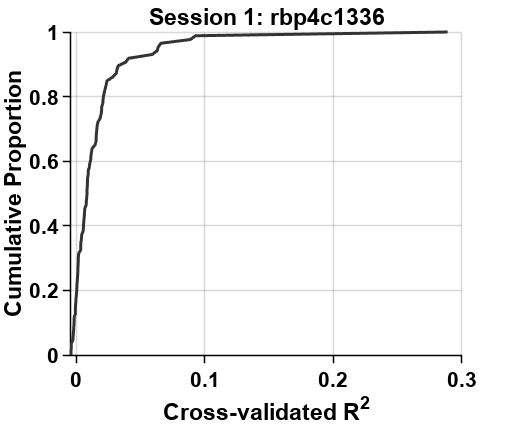

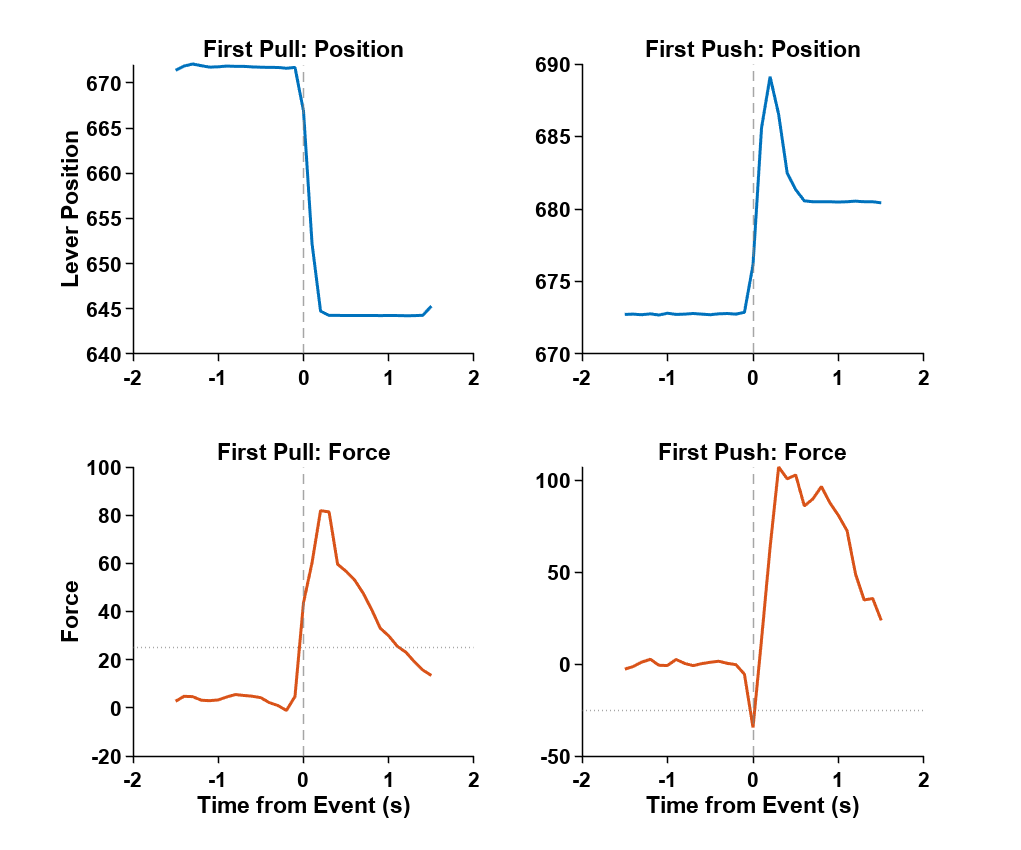

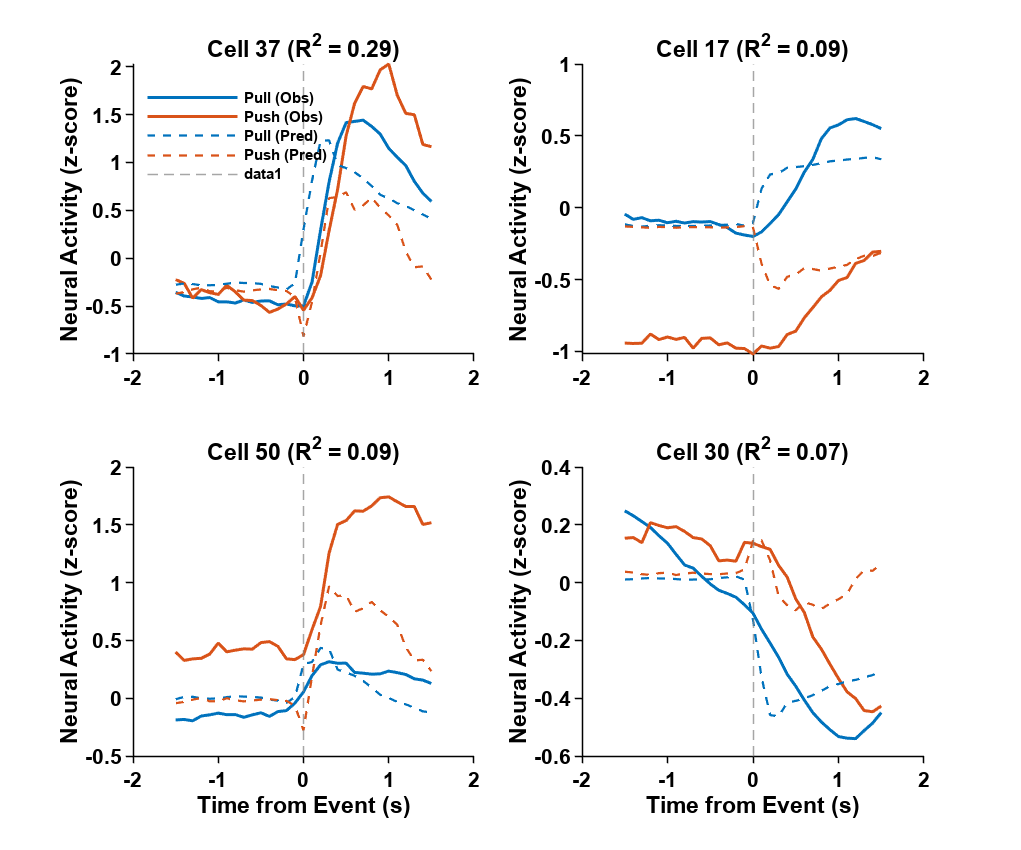

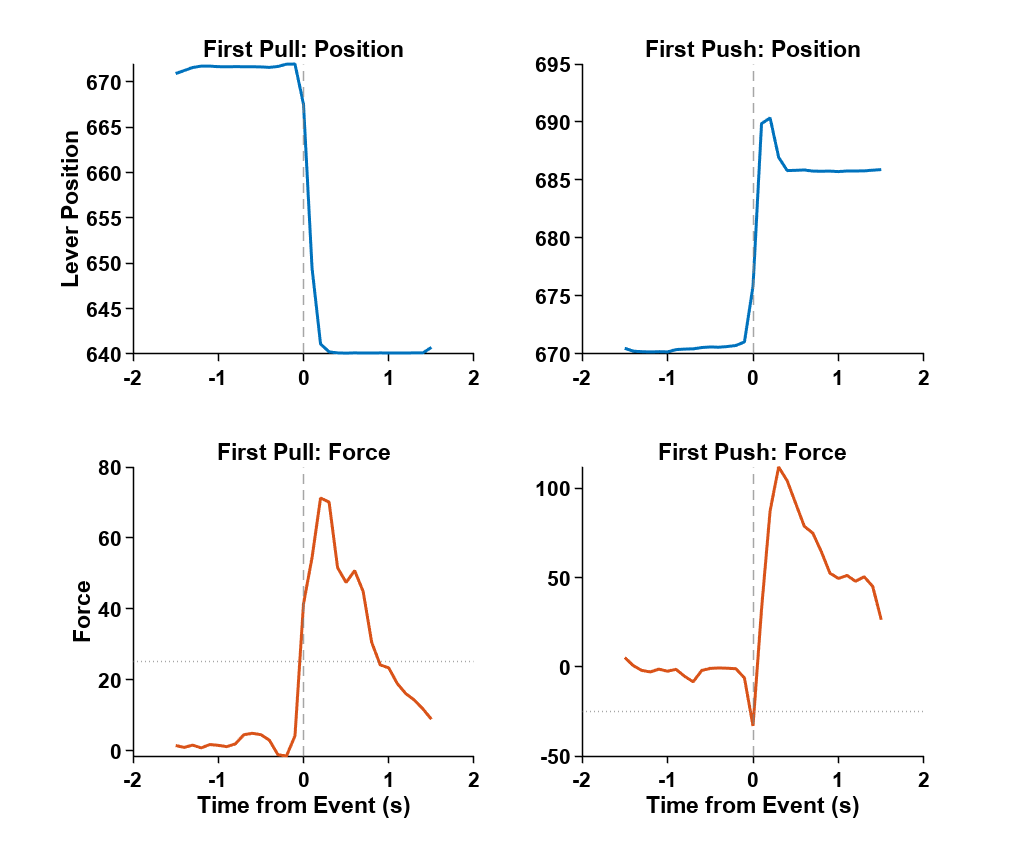

%% --- Linear Regression with Cross-Validation & ETA Analysis ---
% Define window size for Regression and ETA to exactly 1.5 seconds before and after event
eta_window_before = fps * 1.5; 
eta_window_after  = fps * 1.5;
time_vector = (-eta_window_before:eta_window_after) / fps;

% --- Variable Selection Flags ---
use_position = true;  % Set to true to include Lever Position in regression
use_force    = true; % Set to true to include Force in regression

% --- Initialize Aggregation Variables for All Sessions ---
all_sessions_R2 = [];
all_pull_pos_trials = [];
all_pull_force_trials = [];
all_push_pos_trials = [];
all_push_force_trials = [];

for i_session = 1:length(Animal)
    X_all = behavior_dec_data{i_session};
    Y_all = processed_neural_activity_data{i_session};
    
    if isempty(X_all) || isempty(Y_all)
        continue;
    end
    
    % Extract trial numbers, lever positions, and forces
    trials = X_all(:, 2);
    positions = X_all(:, 6);
    forces = X_all(:, 7);
    
    unique_trials_in_session = unique(trials(trials > 0 & ~isnan(trials)));
    
    % Arrays to store event indices for ETA
    pull_event_indices = [];
    push_event_indices = [];
    
    % Loop through each trial to find the first Pull and Push events
    % for i_tr = unique_trials_in_session'
    %     trial_indices = find(trials == i_tr);
    %     trial_forces = forces(trial_indices);
    
    % Loop through each trial to find the first Pull and Push events
    for i_tr = unique_trials_in_session'
        trial_indices = find(trials == i_tr);

        if isempty(trial_indices)
            continue;
        end

        % Filter: Check if reward was delivered within 1 second after the trial ended (8th column equals 1)
        last_trial_idx = trial_indices(end);
        post_trial_start = last_trial_idx + 1;
        post_trial_end = min(size(X_all, 1), last_trial_idx + round(fps));

        % Skip this trial if no reward is detected within the 1-second post-trial window
        if post_trial_start > size(X_all, 1) || ~any(X_all(post_trial_start:post_trial_end, 8) == 1)
            continue;
        end

        trial_forces = forces(trial_indices);        


        % Identify first Pull event (Force > force_thr)
        first_pull = find(trial_forces > force_thr, 1, 'first');
        if ~isempty(first_pull)
            pull_event_indices = [pull_event_indices; trial_indices(first_pull)];
        end
        
        % Identify first Push event (Force < -force_thr)
        first_push = find(trial_forces < -force_thr, 1, 'first');
        if ~isempty(first_push)
            push_event_indices = [push_event_indices; trial_indices(first_push)];
        end

        % % Identify Pull trials and find the peak velocity timing (max positive velocity)
        % if any(trial_forces > force_thr)
        %     pull_candidates = find(trial_velocities < 0);
        %     if ~isempty(pull_candidates)
        %         [min_val, local_idx] = min(trial_velocities(pull_candidates));
        %         peak_pull_v_idx = pull_candidates(local_idx);
        %         pull_event_indices = [pull_event_indices; trial_indices(peak_pull_v_idx)];
        %         all_pull_max_vel = [all_pull_max_vel; abs(min_val)]; % Accumulate peak pull velocity
        %     end
        % end
        % 
        % % Identify Push trials and find the peak velocity timing (max negative velocity)
        % if any(trial_forces < -force_thr)
        %     push_candidates = find(trial_velocities > 0);
        %     if ~isempty(push_candidates)
        %         [max_val, local_idx] = max(trial_velocities(push_candidates));
        %         peak_push_v_idx = push_candidates(local_idx);
        %         push_event_indices = [push_event_indices; trial_indices(peak_push_v_idx)];
        %         all_push_max_vel = [all_push_max_vel; abs(max_val)]; % Accumulate peak push speed as absolute value
        %     end
        % end
        % % Identify Pull trials and find the first timing where displacement >= pos_thr
        % if any(trial_forces > force_thr)
        %     pull_idx = find(trial_displacement <= -pos_thr, 1, 'first');
        %     if ~isempty(pull_idx)
        %         pull_event_indices = [pull_event_indices; trial_indices(pull_idx)];
        %         all_pull_max_vel = [all_pull_max_vel; abs(trial_velocities(pull_idx))]; 
        %     end
        % end
        % 
        % % Identify Push trials and find the first timing where displacement <= -pos_thr
        % if any(trial_forces < -force_thr)
        %     push_idx = find(trial_displacement >= pos_thr, 1, 'first');
        %     if ~isempty(push_idx)
        %         push_event_indices = [push_event_indices; trial_indices(push_idx)];
        %         all_push_max_vel = [all_push_max_vel; abs(trial_velocities(push_idx))]; 
        %     end
        % end

    end
    
    % --- Construct Time Windows for Regression ---
    regression_indices = [];
    all_events = [pull_event_indices; push_event_indices];
    for i_ev = 1:length(all_events)
        ev_idx = all_events(i_ev);
        win_start = max(1, ev_idx - eta_window_before);
        win_end = min(size(X_all, 1), ev_idx + eta_window_after);
        regression_indices = [regression_indices, win_start:win_end];
    end
    regression_indices = unique(sort(regression_indices));
    regression_indices = regression_indices(:); % Convert to column vector
    
    % --- Dynamically build the predictor matrix based on selection flags ---
    X_session_full = [];
    if use_position
        X_session_full = [X_session_full, positions];
    end
    if use_force
        X_session_full = [X_session_full, forces];
    end
    
    if isempty(X_session_full)
        error('At least one predictor (use_position or use_force) must be set to true.');
    end
    
    % Filter predictors and neural responses using the window indices
    X_filtered = X_session_full(regression_indices, :);
    Y_filtered = Y_all(regression_indices, :);
    
    % --- Cross-Validation Setup & Full Model Fitting ---
    n_folds = 5;
    mean_R2 = zeros(1, size(Y_filtered, 2));
    Y_pred_all = zeros(size(Y_all)); 
    
    if size(X_filtered, 1) >= n_folds
        cv = cvpartition(size(X_filtered, 1), 'KFold', n_folds);
        n_cells = size(Y_filtered, 2);
        R2_folds = zeros(n_folds, n_cells);
        
        for i_fold = 1:n_folds
            train_idx = cv.training(i_fold);
            test_idx = cv.test(i_fold);
            
            X_train = X_filtered(train_idx, :); Y_train = Y_filtered(train_idx, :);
            X_test = X_filtered(test_idx, :);   Y_test = Y_filtered(test_idx, :);
            
            X_train_int = [ones(sum(train_idx), 1), X_train];
            X_test_int = [ones(sum(test_idx), 1), X_test];
            
            beta = X_train_int \ Y_train;
            Y_pred = X_test_int * beta;
            
            ss_res = sum((Y_test - Y_pred).^2, 1);
            ss_tot = sum((Y_test - mean(Y_test, 1)).^2, 1);
            
            valid_cells = ss_tot > 0;
            R2_folds(i_fold, valid_cells) = 1 - (ss_res(valid_cells) ./ ss_tot(valid_cells));
        end
        mean_R2 = mean(R2_folds, 1);
        
        % Accumulate R2 values for the summary plot
        all_sessions_R2 = [all_sessions_R2, mean_R2];
        
        % Fit full regression model across all filtered samples to generate continuous predictions
        X_filtered_int = [ones(size(X_filtered, 1), 1), X_filtered];
        beta_full = X_filtered_int \ Y_filtered;
        
        % Predict across the entire session timeline with matching dimensions
        X_all_int = [ones(size(X_session_full, 1), 1), X_session_full];
        Y_pred_all = X_all_int * beta_full;
        
        %% --- Plot 1: Cumulative Distribution Function (ECDF) of R^2 ---
        fig_r2 = figure('Units', 'centimeters', 'Position', [2, 2, 6, 5]);
        [f, x] = ecdf(mean_R2);
        plot(x, f, 'Color', [0.2 0.2 0.2], 'LineWidth', 1);
        
        xlabel('Cross-validated R^2', 'FontSize', 7, 'FontName', 'Arial');
        ylabel('Cumulative Proportion', 'FontSize', 7, 'FontName', 'Arial');
        title(sprintf('Session %d: %s', i_session, Animal{i_session}), 'FontSize', 7, 'FontName', 'Arial');
        grid on;
        set(gca, 'FontName', 'Arial', 'FontSize', 7, 'LineWidth', 0.5, 'Box', 'off', 'TickDir', 'out', ...
            'TickLength', [0.02, 0.02], 'XColor', [0 0 0], 'YColor', [0 0 0], 'GridAlpha', 0.15);
        
        if ~exist(output_dir, 'dir'), mkdir(output_dir); end
        exportgraphics(fig_r2, fullfile(output_dir, sprintf('R2_ecdf_session_%d.pdf', i_session)), 'ContentType', 'vector');
        close(fig_r2);
    else
        warning('Session %d: Insufficient data points for %d-fold CV.', i_session, n_folds);
        continue; 
    end
    
    %% --- ETA (Event-Triggered Average) Calculation ---
    extract_eta = @(events, signal) cell2mat(arrayfun(@(ev) ...
        signal(max(1, ev - eta_window_before) : min(size(signal, 1), ev + eta_window_after), :)', ...
        events(events > eta_window_before & events <= size(signal, 1) - eta_window_after), 'UniformOutput', false));

    % Pull/Push Events ETA for Behavior
    pull_pos_trig = extract_eta(pull_event_indices, positions);
    pull_force_trig = extract_eta(pull_event_indices, forces);
    push_pos_trig = extract_eta(push_event_indices, positions);
    push_force_trig = extract_eta(push_event_indices, forces);
    
    % Accumulate trial-by-trial data across all sessions for collective analysis
    if ~isempty(pull_pos_trig),   all_pull_pos_trials   = [all_pull_pos_trials; pull_pos_trig]; end
    if ~isempty(pull_force_trig), all_pull_force_trials = [all_pull_force_trials; pull_force_trig]; end
    if ~isempty(push_pos_trig),   all_push_pos_trials   = [all_push_pos_trials; push_pos_trig]; end
    if ~isempty(push_force_trig), all_push_force_trials = [all_push_force_trials; push_force_trig]; end
    
    %% --- Plot 2: Behavior & Force ETA ---
    fig_eta = figure('Units', 'centimeters', 'Position', [2, 2, 12, 10]);
    
    subplot(2, 2, 1);
    if ~isempty(pull_pos_trig), plot(time_vector, mean(pull_pos_trig, 1), 'Color', [0 0.4470 0.7410], 'LineWidth', 1); end
    ylabel('Lever Position', 'FontSize', 7, 'FontName', 'Arial'); title('First Pull: Position', 'FontSize', 7, 'FontName', 'Arial');
    xline(0, '--', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5);
    
    subplot(2, 2, 3);
    if ~isempty(pull_force_trig), plot(time_vector, mean(pull_force_trig, 1), 'Color', [0.8500 0.3250 0.0980], 'LineWidth', 1); end
    xlabel('Time from Event (s)', 'FontSize', 7, 'FontName', 'Arial'); ylabel('Force', 'FontSize', 7, 'FontName', 'Arial'); title('First Pull: Force', 'FontSize', 7, 'FontName', 'Arial');
    xline(0, '--', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5); yline(force_thr, ':', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5);
    
    subplot(2, 2, 2);
    if ~isempty(push_pos_trig), plot(time_vector, mean(push_pos_trig, 1), 'Color', [0 0.4470 0.7410], 'LineWidth', 1); end
    title('First Push: Position', 'FontSize', 7, 'FontName', 'Arial');
    xline(0, '--', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5);
    
    subplot(2, 2, 4);
    if ~isempty(push_force_trig), plot(time_vector, mean(push_force_trig, 1), 'Color', [0.8500 0.3250 0.0980], 'LineWidth', 1); end
    xlabel('Time from Event (s)', 'FontSize', 7, 'FontName', 'Arial'); title('First Push: Force', 'FontSize', 7, 'FontName', 'Arial');
    xline(0, '--', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5); yline(-force_thr, ':', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5);
    
    for sp = 1:4
        subplot(2, 2, sp);
        set(gca, 'FontName', 'Arial', 'FontSize', 7, 'LineWidth', 0.5, 'Box', 'off', 'TickDir', 'out', ...
            'TickLength', [0.02, 0.02], 'XColor', [0 0 0], 'YColor', [0 0 0]);
    end
    exportgraphics(fig_eta, fullfile(output_dir, sprintf('Behavior_Force_ETA_session_%d.pdf', i_session)), 'ContentType', 'vector');
    close(fig_eta);

    %% --- Plot 3: Top 4 Neurons ETA (Observed vs Predicted) ---
    [~, sorted_cell_indices] = sort(mean_R2, 'descend');
    top_cells = sorted_cell_indices(1:min(4, length(sorted_cell_indices)));
    
    fig_neural = figure('Units', 'centimeters', 'Position', [2, 2, 12, 10]);
    
    for i_plot = 1:length(top_cells)
        cell_idx = top_cells(i_plot);
        
        cell_activity_obs  = Y_all(:, cell_idx);
        cell_activity_pred = Y_pred_all(:, cell_idx);
        
        pull_neural_obs_trig  = extract_eta(pull_event_indices, cell_activity_obs);
        pull_neural_pred_trig = extract_eta(pull_event_indices, cell_activity_pred);
        push_neural_obs_trig  = extract_eta(push_event_indices, cell_activity_obs);
        push_neural_pred_trig = extract_eta(push_event_indices, cell_activity_pred);
        
        subplot(2, 2, i_plot);
        hold on;
        
        if ~isempty(pull_neural_obs_trig)
            plot(time_vector, mean(pull_neural_obs_trig, 1), 'Color', [0 0.4470 0.7410], 'LineWidth', 1, 'DisplayName', 'Pull (Obs)');
        end
        if ~isempty(push_neural_obs_trig)
            plot(time_vector, mean(push_neural_obs_trig, 1), 'Color', [0.8500 0.3250 0.0980], 'LineWidth', 1, 'DisplayName', 'Push (Obs)');
        end
        
        if ~isempty(pull_neural_pred_trig)
            plot(time_vector, mean(pull_neural_pred_trig, 1), '--', 'Color', [0 0.4470 0.7410], 'LineWidth', 0.75, 'DisplayName', 'Pull (Pred)');
        end
        if ~isempty(push_neural_pred_trig)
            plot(time_vector, mean(push_neural_pred_trig, 1), '--', 'Color', [0.8500 0.3250 0.0980], 'LineWidth', 0.75, 'DisplayName', 'Push (Pred)');
        end
        
        xline(0, '--', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5);
        ylabel('Neural Activity (z-score)', 'FontSize', 7, 'FontName', 'Arial');
        title(sprintf('Cell %d (R^2 = %.2f)', cell_idx, mean_R2(cell_idx)), 'FontSize', 7, 'FontName', 'Arial');
        
        if i_plot >= 3
            xlabel('Time from Event (s)', 'FontSize', 7, 'FontName', 'Arial');
        end
        if i_plot == 1
            legend('show', 'FontSize', 5, 'FontName', 'Arial', 'Box', 'off', 'Location', 'best');
        end
        
        set(gca, 'FontName', 'Arial', 'FontSize', 7, 'LineWidth', 0.5, 'Box', 'off', 'TickDir', 'out', ...
            'TickLength', [0.02, 0.02], 'XColor', [0 0 0], 'YColor', [0 0 0]);
    end
    
    exportgraphics(fig_neural, fullfile(output_dir, sprintf('Top4_Neurons_ETA_session_%d.pdf', i_session)), 'ContentType', 'vector');
    close(fig_neural);
end


%% ========================================================================
%  --- All Sessions Summary Plots ---
%  ========================================================================

%% --- Summary Plot 1: Collective R^2 ECDF across All Sessions ---
if ~isempty(all_sessions_R2)
    fig_summary_r2 = figure('Units', 'centimeters', 'Position', [2, 2, 6, 5]);
    [f_all, x_all] = ecdf(all_sessions_R2);
    plot(x_all, f_all, 'Color', [0 0 0], 'LineWidth', 1.2);
    
    xlabel('Cross-validated R^2', 'FontSize', 7, 'FontName', 'Arial');
    ylabel('Cumulative Proportion', 'FontSize', 7, 'FontName', 'Arial');
    title(sprintf('All Sessions Combined (n = %d cells)', length(all_sessions_R2)), 'FontSize', 7, 'FontName', 'Arial');
    grid on;
    xlim([-0.025, 0.1]);
    set(gca, 'FontName', 'Arial', 'FontSize', 7, 'LineWidth', 0.5, 'Box', 'off', 'TickDir', 'out', ...
        'TickLength', [0.02, 0.02], 'XColor', [0 0 0], 'YColor', [0 0 0], 'GridAlpha', 0.15);
    
    exportgraphics(fig_summary_r2, fullfile(output_dir, 'R2_ecdf_all_sessions.pdf'), 'ContentType', 'vector');
    close(fig_summary_r2);
end

%% --- Summary Plot 2: Collective Behavior & Force ETA with SEM ---
fig_summary_eta = figure('Units', 'centimeters', 'Position', [2, 2, 12, 10]);

% Subplot 1: Combined Position during Pull
subplot(2, 2, 1);
if ~isempty(all_pull_pos_trials)
    hold on;
    mu = mean(all_pull_pos_trials, 1);
    sem = std(all_pull_pos_trials, 0, 1) / sqrt(size(all_pull_pos_trials, 1));
    fill([time_vector, fliplr(time_vector)], [mu + sem, fliplr(mu - sem)], [0 0.4470 0.7410], ...
         'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    plot(time_vector, mu, 'Color', [0 0.4470 0.7410], 'LineWidth', 1);
end
ylabel('Lever Position', 'FontSize', 7, 'FontName', 'Arial'); title('All Sessions: Pull Position', 'FontSize', 7, 'FontName', 'Arial');
xline(0, '--', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5);

% Subplot 2: Combined Position during Push
subplot(2, 2, 2);
if ~isempty(all_push_pos_trials)
    hold on;
    mu = mean(all_push_pos_trials, 1);
    sem = std(all_push_pos_trials, 0, 1) / sqrt(size(all_push_pos_trials, 1));
    fill([time_vector, fliplr(time_vector)], [mu + sem, fliplr(mu - sem)], [0 0.4470 0.7410], ...
         'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    plot(time_vector, mu, 'Color', [0 0.4470 0.7410], 'LineWidth', 1);
end
title('All Sessions: Push Position', 'FontSize', 7, 'FontName', 'Arial');
xline(0, '--', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5);

% Subplot 3: Combined Force during Pull
subplot(2, 2, 3);
if ~isempty(all_pull_force_trials)
    hold on;
    mu = mean(all_pull_force_trials, 1);
    sem = std(all_pull_force_trials, 0, 1) / sqrt(size(all_pull_force_trials, 1));
    fill([time_vector, fliplr(time_vector)], [mu + sem, fliplr(mu - sem)], [0.8500 0.3250 0.0980], ...
         'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    plot(time_vector, mu, 'Color', [0.8500 0.3250 0.0980], 'LineWidth', 1);
end
xlabel('Time from Event (s)', 'FontSize', 7, 'FontName', 'Arial'); ylabel('Force', 'FontSize', 7, 'FontName', 'Arial'); title('All Sessions: Pull Force', 'FontSize', 7, 'FontName', 'Arial');
xline(0, '--', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5); yline(force_thr, ':', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5);

% Subplot 4: Combined Force during Push
subplot(2, 2, 4);
if ~isempty(all_push_force_trials)
    hold on;
    mu = mean(all_push_force_trials, 1);
    sem = std(all_push_force_trials, 0, 1) / sqrt(size(all_push_force_trials, 1));
    fill([time_vector, fliplr(time_vector)], [mu + sem, fliplr(mu - sem)], [0.8500 0.3250 0.0980], ...
         'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    plot(time_vector, mu, 'Color', [0.8500 0.3250 0.0980], 'LineWidth', 1);
end
xlabel('Time from Event (s)', 'FontSize', 7, 'FontName', 'Arial'); title('All Sessions: Push Force', 'FontSize', 7, 'FontName', 'Arial');
xline(0, '--', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5); yline(-force_thr, ':', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5);

% Apply uniform format constraints to all grid elements
for sp = 1:4
    subplot(2, 2, sp);
    set(gca, 'FontName', 'Arial', 'FontSize', 7, 'LineWidth', 0.5, 'Box', 'off', 'TickDir', 'out', ...
        'TickLength', [0.02, 0.02], 'XColor', [0 0 0], 'YColor', [0 0 0]);
end

exportgraphics(fig_summary_eta, fullfile(output_dir, 'Behavior_Force_ETA_all_sessions.pdf'), 'ContentType', 'vector');
close(fig_summary_eta);

% linear decoding analysis
seed_num = 1;
l23_Rs = cell(1,length(Animal));
l5_Rs  = cell(1,length(Animal));

for i_session = 1:length(Animal)  
    standarized_neural_activity_data_train = zscore_columns(processed_dec_neural_activity_data_train{i_session});
    standarized_neural_activity_data_test  = zscore_columns(processed_dec_neural_activity_data_test{i_session});
    layer23_cells_train = processed_dec_neural_activity_data_train{i_session}(:,find(pointAreas_data{i_session} == 1));
    layer5_cells_train  = processed_dec_neural_activity_data_train{i_session}(:,find(pointAreas_data{i_session} == 0));
    layer23_cells_test  = processed_dec_neural_activity_data_test{i_session}(:,find(pointAreas_data{i_session} == 1));
    layer5_cells_test   = processed_dec_neural_activity_data_test{i_session}(:,find(pointAreas_data{i_session} == 0));
    num_vars = size(behavior_dec_train{i_session}, 2);
    l23_Rs_session = zeros(5, seed_num, num_vars);
    l5_Rs_session  = zeros(5, seed_num, num_vars);
    % l23_Rs_session = zeros(5,seed_num,13); % 13; variable num of behavior and Bayes related
    % l5_Rs_session = zeros(5,seed_num,13);
    for k_cells = 1:5
        for j_seed = 1:seed_num %:10
            rng(j_seed);
            
            try
                layer23_idx = randperm(size(layer23_cells_train,2),2^(k_cells+2));
                layer23_train = layer23_cells_train(:,layer23_idx);
                layer23_test  = layer23_cells_test(:,layer23_idx);
            catch
                layer23_idx = [];
                layer23_train = NaN;
                layer23_test = NaN;
                l23_Rs_session(k_cells,j_seed,:) = NaN; % layer23にNaNを代入
            end
            
            try
                layer5_idx  = randperm(size(layer5_cells_train,2),2^(k_cells+2));
                layer5_train  = layer5_cells_train(:,layer5_idx);
                layer5_test   = layer5_cells_test(:,layer5_idx);
            catch
                layer5_idx = [];
                layer5_train = NaN;
                layer5_test = NaN;
                l5_Rs_session(k_cells,j_seed,:)  = NaN; % layer5にNaNを代入
            end
            
            % % preprocess to use undeconvolved behavior data and state and action value
            % % of each taken state and action
            % state_value_dec  = state_value_neural_time_dec;
            % action_value_dec = action_value_neural_time_dec;
            % behavior_dec_data = [behavior_neural_time state_value_dec action_value_dec];
            % % drop nan
            % behavior_dec_data(nan_time,:) = [];
            % behavior_dec_train = behavior_dec_data(idxTrain,:);
            % behavior_dec_test  = behavior_dec_data(idxTest,:);
            % % standarize input and output
            % behavior_dec_train = zscore_columns(behavior_dec_train);
            % behavior_dec_test  = zscore_columns(behavior_dec_test);
            behavior_dec_train_session = behavior_dec_train{i_session};
            behavior_dec_test_session = behavior_dec_test{i_session};
            
            % construct linear decoder to predict behavior and task variables
            if ~isempty(layer23_idx)
                for i_beh_val = 1:size(behavior_dec_train_session,2)
                    layer23_model = ridge(behavior_dec_train_session(:,i_beh_val),layer23_train,0.01,0);
                    layer23_ypred = layer23_model(1) + layer23_test*layer23_model(2:end);
                    [~, ~, l23_R] = regression_accuracy(behavior_dec_test_session(:,i_beh_val),layer23_ypred);
                    l23_Rs_session(k_cells,j_seed,i_beh_val) = l23_R;
                end
            end
            
            if ~isempty(layer5_idx)
                for i_beh_val = 1:size(behavior_dec_train_session,2)
                    layer5_model  = ridge(behavior_dec_train_session(:,i_beh_val),layer5_train,0.01,0);
                    layer5_ypred  = layer5_model(1) + layer5_test*layer5_model(2:end);
                    [~, ~, l5_R]  = regression_accuracy(behavior_dec_test_session(:,i_beh_val),layer5_ypred);
                    l5_Rs_session(k_cells,j_seed,i_beh_val)  = l5_R;
                end
            end
        end
    end
    l23_Rs{i_session} = l23_Rs_session;    
    l5_Rs{i_session} = l5_Rs_session; 
end

Index in position 2 exceeds array bounds.

size(l23_Rs{1})
% l23_state_value_R_std
% l5_state_value_R_std

% plot decoding results
if bayes == true
    titles = {'Trial start', 'Trial end', 'Resistance', 'Position', 'Force', 'Reward', 'licking',...
        'Pull Resistance','Push Resistance','Pull obs.','Push obs.','Pull likelihood','Push likelihood','Pull posterior','Push posterior','Pull prediction error','Push prediction error'}; 
elseif state_action_value == true
    titles = {'Trial start', 'Trial end', 'Resistance', 'Position', 'Force', 'Reward', 'licking','Pull Resistance', 'Push Resistance', 'V(s)','Q(s,a)'};
else
    titles = {'Trial start', 'Trial end', 'Resistance', 'Position', 'Force', 'Reward', 'licking','Pull Resistance', 'Push Resistance'};  
end
for i = 1:length(titles)
    % Collect data from all cell arrays
    l23_data = [];
    l5_data = [];
    for k = 1:length(Animal) 
        l23_data = cat(2, l23_data, l23_Rs{k}(:,:,i+2)); % (条件数 x 繰り返し数) を繰り返し方向に結合
        l5_data = cat(2, l5_data, l5_Rs{k}(:,:,i+2));
    end
    % 平均と標準偏差を計算
    i_l23_R = nanmean(l23_data, 2);
    i_l23_R_std = nanstd(l23_data, 0, 2);
    i_l5_R = nanmean(l5_data, 2);
    i_l5_R_std = nanstd(l5_data, 0, 2);
    
    figure
    x = [8,16,32,64,128];
    hold on;
    errorbar(x,i_l23_R,i_l23_R_std,'-o','Color','g','LineWidth',1.5,'MarkerSize',8);
    errorbar(x,i_l5_R,i_l5_R_std,'-o','Color','b','LineWidth',1.5,'MarkerSize',8);
    set(gca,'Xscale','log');
    title([titles{i}]);
    hold off;
    legend({'layer23','layer5'},'Location','northwest');
    xlabel('Number of cells');
    ylabel('Decoding accuracy (r)');
    filename = [output_dir titles{i} '_decoding_accuracy.png'];    
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_')  '_' titles{i} '_decoding_accuracy.png'];
    saveas(gcf,filename);
end

% % Statistical test
% % Two-way ANOVA posthoc Tukey
% 
% for i = 1:length(titles)
%     if i == 3
%         continue;
%     end
%     % Collect data from all cell arrays
%     l23_data = [];
%     l5_data = [];
%     for k = 1:length(Animal)
%         l23_data = cat(2, l23_data, l23_Rs{k}(:,:,i+2)); % (条件数 x 繰り返し数) を繰り返し方向に結合
%         l5_data = cat(2, l5_data, l5_Rs{k}(:,:,i+2));
%     end
%     % データを整形
%     l23_data_t = l23_data';
%     l5_data_t = l5_data';
%     data = [l23_data_t; l5_data_t]; % (繰り返し数 x 条件数)
%     data_vector = data(:); % ベクトル化
% 
%     % 因子を作成
%     num_repeats = size(l23_data_t,1); % 繰り返し数
%     num_conditions = size(l23_data_t,2); % 条件数
%     total_samples = num_repeats * 2 * num_conditions; % 合計サンプル数
% 
%     factor1 = [repmat({'L23'}, num_repeats,num_conditions); repmat({'L5'}, num_repeats,num_conditions)];
%     factor2_labels = {'8cells','16cells','32cells','64cells','128cells'};
%     factor2_per_repeat = repmat(factor2_labels, num_repeats,1);
%     factor2 = [factor2_per_repeat; factor2_per_repeat];
%     factor1 = factor1(:); factor2 = factor2(:);
% 
%     % NaNを含むエントリを削除
%     valid_idx = ~isnan(data_vector);
%     data_vector = data_vector(valid_idx);
%     factor1 = factor1(valid_idx);
%     factor2 = factor2(valid_idx);
% 
%     % グループごとの平均と分散を計算
%     [group_mean, group_std, group_names] = grpstats(data_vector, {factor1, factor2}, {'mean', 'std','gname'});
% 
%     % 結果をテーブルにまとめる
%     stats_table = table;
%     stats_table.Layer = group_names(:,1);
%     stats_table.Num_of_Cells = group_names(:,2);
%     stats_table.Mean = group_mean(:);
%     stats_table.Standard_Deviation = group_std(:);
% 
%     combined_factors = strcat(factor1,'_', factor2);  % factor1とfactor2を結合して新しいカテゴリ変数を作成
%     % Kruskal-Wallis 検定を実行
%     % Dunnの多重比較を実行
%     [p, tbl, stats] = kruskalwallis(data_vector, combined_factors, 'off');
%     [c, m, h, nms] = multcompare(stats, 'CType', 'dunn-sidak');
%     % [p, tbl, stats] = anovan(data_vector, {factor1, factor2}, 'varnames', {'layer','num_of_cells'}, 'display', 'off');
%     % [c, m, h, nms]  = multcompare(stats, 'dimension', [1,2], 'display', 'off');
% 
%     disp(titles{i});
%     disp('Group Statistics (Mean and STD):');
%     disp(stats_table);
%     disp('Kruskal-Wallis:');
%     disp(tbl);
%     disp('dunn-sidak multi comparison:');
%     tbl2 = array2table(c,"VariableNames",["Group1","Group2","Lower Limit","A-B","Upper Limit","P-value"]);
%     tbl2.("Group1")=nms(tbl2.("Group1"));
%     tbl2.("Group2")=nms(tbl2.("Group2"));
%     disp(tbl2);
%     ANOVA_filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_')  '_' titles{i} '_ANOVA.csv'];
%     writecell(tbl, ANOVA_filename);
%     Tukey_filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_')  '_' titles{i} '_Tukey.csv'];
%     writetable(tbl2, Tukey_filename);
% 
%     % グループ統計をCSVファイルに保存
%     stats_filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_')  '_' titles{i} '_GroupStats.csv'];
%     writetable(stats_table, stats_filename);
% end

% % 可視化対象のセッション・細胞数・seed を選択
% i_session = 1;
% k_cells = 2;   % 例：2^5 = 32細胞
% j_seed = 1;
% 
% % 再現可能なランダム選択（layer5）
% rng(j_seed);
% layer5_idx = randperm(size(layer5_cells_train,2), 2^(k_cells+2));
% layer5_train = layer5_cells_train(:, layer5_idx);
% layer5_test  = layer5_cells_test(:, layer5_idx);
% 
% % テスト用行動変数データ
% true_behavior_all = behavior_dec_test{i_session};
% train_behavior_all = behavior_dec_train{i_session};
% 
% % 行動変数の数
% n_behaviors = size(true_behavior_all, 2);
% 
% % 図を作成
% figure('Position', [100, 100, 1400, 300 + 250*ceil(n_behaviors/2)]);
% t = 1:size(true_behavior_all, 1);  % 時間軸
% 
% for i_beh_val = 1:n_behaviors-2
%     % モデル構築と予測
%     layer5_model = ridge(train_behavior_all(:, i_beh_val), layer5_train, 0.01, 0);
%     layer5_ypred = layer5_model(1) + layer5_test * layer5_model(2:end);
%     true_behavior = true_behavior_all(:, i_beh_val);
% 
%     % subplot にプロット
%     subplot(ceil(n_behaviors/2), 2, i_beh_val);
%     plot(t, true_behavior, 'k', 'LineWidth', 1.2); hold on;
%     plot(t, layer5_ypred, 'r--', 'LineWidth', 1.2);
%     xlabel('Time (frame)');
%     ylabel(sprintf('Var %d', i_beh_val));
%     title(sprintf('Behavior %d (Layer 5, %d cells)', i_beh_val, 2^(k_cells+2)));
%     legend('True', 'Predicted');
% end
% 
% sgtitle(sprintf('Layer 5 - Behavior Prediction (Session %d, Seed %d, %d cells)', ...
%     i_session, j_seed, 2^(k_cells+2)));

% パラメータ
n_neurons_list = [8, 16, 32, 64];
idx_32cells = find(n_neurons_list == 32); % 32細胞のインデックス
num_animals = length(Animal);
num_folds = 10;
window_trials = 20; % 前後20トライアル
relative_trials = -window_trials : (window_trials - 1);
all_reversal_acc_L23 = [];
all_reversal_acc_L5  = [];
all_reversal_behav_acc = [];
all_reversal_behav_cons = [];

if decoder_SVM
    template = templateSVM('KernelFunction', 'gaussian', 'KernelScale', 'auto');
else
    template = templateLinear('Learner', 'logistic', 'Regularization', 'ridge');
end

% --- 結果を格納するための構造体を初期化 ---
results(num_animals) = struct();
results_cross(num_animals) = struct();
trial_group_names = {'all_valid', 'straight', 'corrected'};
label_names = {'choice_correct', 'choice_pred', 'choice_error', 'reward_amount', 'reward_pred', 'reward_error', 'first_choice', 'final_choice'};
if strcmp(block, 'Value')
    labels_to_decode = [1, 5, 7, 8]; % 2 (choice_pred) の代わりに 5 (reward_pred)
else
    labels_to_decode = [1, 2, 7, 8]; % デフォルト
end

% % =========================================================================
% % GLM-HMMデータの読み込みとStateグループの追加
% % =========================================================================
% if exist('GLM_HMM', 'var') && GLM_HMM
%     glm_hmm_file = [strjoin(data_folders(1)) filesep 'glm_hmm_states_all_sessions.csv']; 
%     if isfile(glm_hmm_file)
%         glm_hmm_data = readtable(glm_hmm_file);
%         unique_glm_sessions = unique(glm_hmm_data.Session_ID);
%         num_glm_states = length(unique(glm_hmm_data.Max_State));
% 
%         % trial_group_names に GLM-HMM の状態を追加
%         for s = 1:num_glm_states
%             trial_group_names{end+1} = sprintf('state_%d', s-1);
%         end
%         disp('GLM-HMMデータを読み込み、試行グループに各Stateを追加しました。');
%     else
%         warning('glm_hmm_states_all_sessions.csv が見つかりません。GLM-HMM解析をスキップします。');
%         GLM_HMM = false;
%     end
% end
% % =========================================================================

% --- メインループ ---
for i_animal = 1:num_animals
    
    fprintf('\n--- Processing Animal %d of %d ---\n', i_animal, num_animals);
    
    % --- 1. 事前に全ての3Dデータを作成 ---
    before_start_3d = cat(3, before_trial_start_act{i_animal}{2:end-1});
    after_start_3d  = cat(3, after_trial_start_act{i_animal}{2:end-1});
    before_end_3d   = cat(3, before_trial_end_act{i_animal}{2:end-1});
    before_force_3d = cat(3, before_initial_force_act{i_animal}{2:end-1});
    after_force_3d  = cat(3, after_initial_force_act{i_animal}{2:end-1});
    
    % --- 2. デコード対象のラベルと試行グループを定義 ---
    % labels_to_decode = [1, 2, 7, 8];
    
    % 試行グループのインデックスを作成
    all_labels_raw = behavior_cat_dec_data{i_animal}(2:end-1, :);
    straight_trials_mask = (all_labels_raw(:,7) == all_labels_raw(:,8));
    corrected_trials_mask = (all_labels_raw(:,7) ~= all_labels_raw(:,8));
    
    trial_group_masks = {true(size(all_labels_raw,1),1), straight_trials_mask, corrected_trials_mask};
    
    % % =========================================================================
    % % GLM-HMMの状態に基づくトライアルマスクの追加
    % % =========================================================================
    % if exist('GLM_HMM', 'var') && GLM_HMM
    %     session_glm_data = glm_hmm_data(glm_hmm_data.Session_ID == unique_glm_sessions(i_animal), :);
    % 
    %     % デコーディング用データに合わせて両端のトライアル(2:end-1)の抽出
    %     sess_max_state = session_glm_data.Max_State(2:end-1); 
    % 
    %     for s = 1:num_glm_states
    %         state_val = s - 1;
    %         trial_group_masks{end+1} = (sess_max_state == state_val);
    %     end
    % end
    % % =========================================================================
    % ニューロンの層情報を取得
    pointAreas = pointAreas_data{i_animal};
    l23_idx_all = find(pointAreas == 1);
    l5_idx_all  = find(pointAreas == 0);

    % --- 3. ネストしたループで各条件のデコーディングを実行 ---
    for i_group = 1:length(trial_group_names)
        current_group_name = trial_group_names{i_group};
        
        for j_label_val = labels_to_decode
            current_label_name = label_names{j_label_val};
            
            fprintf('  Group: %s, Label: %s\n', current_group_name, current_label_name);

            % a. ラベルに応じて使用する神経活動データを選択
            switch j_label_val
                case 1 % choice_correct
                    neural_data_3d = after_start_3d;
                case {2, 5} % choice_pred または reward_pred
                    neural_data_3d = before_start_3d;
                case 7 % first_choice
                    neural_data_3d = before_force_3d; 
                    % neural_data_3d = after_start_3d;                    
                case 8      % final_choice
                    neural_data_3d = after_force_3d;
                    % neural_data_3d = before_end_3d;
            end
            
            % b. ラベルデータとNaNマスクを作成
            labels_raw = all_labels_raw(:, j_label_val);
            nan_mask = isnan(labels_raw);
            
            % c. 現在の試行グループとNaNマスクを組み合わせて最終的なインデックスを決定
            final_trial_mask = trial_group_masks{i_group} & ~nan_mask;
            
            % d. 最終的なインデックスでデータとラベルをフィルタリング
            labels_final = labels_raw(final_trial_mask);
            data_final_3d = neural_data_3d(:, :, final_trial_mask);
            
            % 有効な試行がなければスキップ
            if isempty(labels_final) || length(unique(labels_final)) < 2
                fprintf('    -> Skipping, not enough valid trials or classes.\n');
                continue;
            end
            
            % e. 補助関数を呼び出してデコーディングを実行
            rng_seed_offset = j_label_val*10 + i_animal*100 + i_group*1000;
            
            [acc_l23, f1_l23] = run_decoding(data_final_3d, labels_final, l23_idx_all, n_neurons_list, template, num_folds, rng_seed_offset);
            [acc_l5,  f1_l5]  = run_decoding(data_final_3d, labels_final, l5_idx_all,  n_neurons_list, template, num_folds, rng_seed_offset + 500);
            
            % f. 結果を構造体に保存
            results(i_animal).L23.(current_group_name).(current_label_name).accuracy = acc_l23;
            results(i_animal).L23.(current_group_name).(current_label_name).f1_score = f1_l23;
            results(i_animal).L5.(current_group_name).(current_label_name).accuracy = acc_l5;
            results(i_animal).L5.(current_group_name).(current_label_name).f1_score = f1_l5;
        end
    end
    % =========================================================================
    % 追加解析: ブロック切り替わり（0.8 ↔ 0.2）前後のデコーディング性能推移
    % =========================================================================
    
    % 今回は例として「first_choice（力に基づく選択）」に対応するデータとラベルを使用
    % 解析したいターゲット（choice_correct等）に応じて neural_data_3d と labels_raw を変更してください
    neural_data_3d_rev = before_start_3d; 
    if strcmp(block, 'Value')
        labels_raw_rev     = all_labels_raw(:, 5); % 5: reward_pred
    else
        labels_raw_rev     = all_labels_raw(:, 2); % choice_pred
    end    
    
    num_actual_trials = length(labels_raw_rev);

    trial_acc_l23 = NaN(num_actual_trials, 1);
    trial_acc_l5  = NaN(num_actual_trials, 1);

    if length(unique(labels_raw_rev(~isnan(labels_raw_rev)))) >= 2
        cv = cvpartition(labels_raw_rev(~isnan(labels_raw_rev)), 'KFold', num_folds);
        
        % L2/3 32細胞
        if length(l23_idx_all) >= 32
            pred_l23 = labels_raw_rev;
            valid_idxs = find(~isnan(labels_raw_rev));
            for i_fold = 1:num_folds
                train_mask = cv.training(i_fold);
                test_mask = cv.test(i_fold);
                
                % 32細胞をランダム抽出（固定シード）
                rng(rng_seed_offset);
                sub_cells = l23_idx_all(randperm(length(l23_idx_all), 32));
                
                % 3Dデータを2D（特徴量×試行）に平坦化
                train_data = neural_data_3d_rev(:, sub_cells, valid_idxs(train_mask));
                train_X = reshape(train_data, [], sum(train_mask))';
                train_Y = labels_raw_rev(valid_idxs(train_mask));
                
                test_data = neural_data_3d_rev(:, sub_cells, valid_idxs(test_mask));
                test_X = reshape(test_data, [], sum(test_mask))';
                
                mdl = fitcecoc(train_X, train_Y, 'Learners', template);
                pred_l23(valid_idxs(test_mask)) = predict(mdl, test_X);
            end
            trial_acc_l23 = double(pred_l23 == labels_raw_rev);
            trial_acc_l23(isnan(labels_raw_rev)) = NaN;
        end
        
        % L5 32細胞
        if length(l5_idx_all) >= 32
            pred_l5 = labels_raw_rev;
            valid_idxs = find(~isnan(labels_raw_rev));
            for i_fold = 1:num_folds
                train_mask = cv.training(i_fold);
                test_mask = cv.test(i_fold);
                
                rng(rng_seed_offset + 500);
                sub_cells = l5_idx_all(randperm(length(l5_idx_all), 32));
                
                train_data = neural_data_3d_rev(:, sub_cells, valid_idxs(train_mask));
                train_X = reshape(train_data, [], sum(train_mask))';
                train_Y = labels_raw_rev(valid_idxs(train_mask));
                
                test_data = neural_data_3d_rev(:, sub_cells, valid_idxs(test_mask));
                test_X = reshape(test_data, [], sum(test_mask))';
                
                mdl = fitcecoc(train_X, train_Y, 'Learners', template);
                pred_l5(valid_idxs(test_mask)) = predict(mdl, test_X);
            end
            trial_acc_l5 = double(pred_l5 == labels_raw_rev);
            trial_acc_l5(isnan(labels_raw_rev)) = NaN;
        end
    end
    
    % 2. pushCorrectの切り替わりポイントを検出 (0.8 -> 0.2 または 0.2 -> 0.8)
    % behavior_cat_dec_data の計算に使った元のブロック情報（pushCorrect）を参照
    % 両端を落とした 2:end-1 の範囲に合わせます
    
    reversal_points = [];
    if strcmp(block, 'Value')
        current_reward_amt = all_labels_raw(2:end-1, 5); 
        for t = 2:length(current_reward_amt)
            r_prev = current_reward_amt(t-1);
            r_curr = current_reward_amt(t);
            if ((r_prev == 3 && r_curr == 1) || (r_prev == 1 && r_curr == 3))
                reversal_points = [reversal_points; t]; 
            end
        end
    else
        % デフォルト: choice_pred (インデックス2) が 0.8->0.2 または 0.2->0.8 に切り替わるタイミング
        current_pushCorrect = all_labels_raw(2:end-1, 2); 
        for t = 2:length(current_pushCorrect)
            p_prev = current_pushCorrect(t-1);
            p_curr = current_pushCorrect(t);
            if ((p_prev == 0.8 && p_curr == 0.2) || (p_prev == 0.2 && p_curr == 0.8))
                reversal_points = [reversal_points; t]; 
            end
        end
    end
    
    % 3. 切り替わり前後のウィンドウ切り出し
    for i_rev = 1:length(reversal_points)
        rev_idx = reversal_points(i_rev);
        
        % 前後20試行のインデックス範囲
        start_idx = rev_idx - window_trials;
        end_idx   = rev_idx + window_trials - 1;
        
        % セッションのインデックス範囲内にある場合のみ抽出
        if start_idx >= 1 && end_idx <= num_actual_trials
            chunk_l23 = trial_acc_l23(start_idx:end_idx);
            chunk_l5  = trial_acc_l5(start_idx:end_idx);
            
            % 全セッション（全切り替わり点）のデータを蓄積
            all_reversal_acc_L23 = [all_reversal_acc_L23; chunk_l23'];
            all_reversal_acc_L5  = [all_reversal_acc_L5; chunk_l5'];
        end
    end

    % =========================================================================
    % 追加解析: ブロック間クロスデコーディング (1つ目 ↔ 2つ目のブロック群)
    % =========================================================================
    
    % ブロック情報の取得 (all_labels_raw(:, 2) = pushCorrect)
    if strcmp(block, 'Value')
        block_labels = all_labels_raw(:, 5); % 5: reward_pred (3 or 1)
        target_val_A = 3; target_val_B = 1;
    else
        block_labels = all_labels_raw(:, 2); % 2: choice_pred (0.8 or 0.2)
        target_val_A = 0.8; target_val_B = 0.2;
    end
    
    % 0.8または0.2が連続しているブロックのインデックスを抽出
    % ラン（連続する同一値の塊）の開始と終了を検出
    run_diff = diff([0; block_labels]);
    run_starts = find(run_diff ~= 0);
    run_ends = [run_starts(2:end) - 1; length(block_labels)];
    
    % 各ブロックの情報を整理
    blocks_A = []; % [開始, 終了]
    blocks_B = [];
    
    for i_run = 1:length(run_starts)
        val = block_labels(run_starts(i_run));
        if val == target_val_A
            blocks_A = [blocks_A; run_starts(i_run), run_ends(i_run)];
        elseif val == target_val_B
            blocks_B = [blocks_B; run_starts(i_run), run_ends(i_run)];
        end
    end
    
    % 1つ目と2つ目のブロックペアが両方の条件で存在するかチェック
    if size(blocks_A, 1) >= 2 && size(blocks_B, 1) >= 2
        idx_block1 = [blocks_A(1,1):blocks_A(1,2), blocks_B(1,1):blocks_B(1,2)];
        idx_block2 = [blocks_A(2,1):blocks_A(2,2), blocks_B(2,1):blocks_B(2,2)];
        
        for j_label_val = labels_to_decode
            current_label_name = label_names{j_label_val};
            
            switch j_label_val
                case 1, neural_data_3d = after_start_3d;
                case {2, 5}, neural_data_3d = before_start_3d;
                case 7, neural_data_3d = before_force_3d;
                case 8, neural_data_3d = after_force_3d;
            end
            
            labels_raw = all_labels_raw(:, j_label_val);
            
            for k_idx = 1:length(n_neurons_list)
                n_cells = n_neurons_list(k_idx);
                
                % --- L2/3 のデコーディング ---
                if length(l23_idx_all) >= n_cells
                    rng(j_label_val*10 + i_animal*100 + k_idx);
                    sub_cells = l23_idx_all(randperm(length(l23_idx_all), n_cells));
                    
                    acc12 = run_cross_decoding(neural_data_3d, labels_raw, idx_block1, idx_block2, sub_cells, template);
                    acc21 = run_cross_decoding(neural_data_3d, labels_raw, idx_block2, idx_block1, sub_cells, template);
                    
                    results_cross(i_animal).L23.(current_label_name).accuracy(k_idx) = (acc12 + acc21) / 2;
                else
                    results_cross(i_animal).L23.(current_label_name).accuracy(k_idx) = NaN;
                end
                
                % --- L5 のデコーディング ---
                if length(l5_idx_all) >= n_cells
                    rng(j_label_val*10 + i_animal*100 + k_idx + 500);
                    sub_cells = l5_idx_all(randperm(length(l5_idx_all), n_cells));
                    
                    acc12 = run_cross_decoding(neural_data_3d, labels_raw, idx_block1, idx_block2, sub_cells, template);
                    acc21 = run_cross_decoding(neural_data_3d, labels_raw, idx_block2, idx_block1, sub_cells, template);
                    
                    results_cross(i_animal).L5.(current_label_name).accuracy(k_idx) = (acc12 + acc21) / 2;
                else
                    results_cross(i_animal).L5.(current_label_name).accuracy(k_idx) = NaN;
                end
            end
        end
    else
        for j_label_val = labels_to_decode
            current_label_name = label_names{j_label_val};
            results_cross(i_animal).L23.(current_label_name).accuracy = NaN(1, length(n_neurons_list));
            results_cross(i_animal).L5.(current_label_name).accuracy  = NaN(1, length(n_neurons_list));
        end
    end
    % =========================================================================
    % 追加解析: ブロック切り替わり前後の「行動データ」の抽出
    % =========================================================================
    % データの定義（両端を除いた 2:end-1 の範囲）
    behav_correct = all_labels_raw(:, 1); % choice_correct (1 or 0)
    % behav_block   = all_labels_raw(:, 2); % choice_pred (0.8 or 0.2)
    behav_choice  = all_labels_raw(:, 8); % final_choice (1 or -1)

    % choice_correctが1かつfinal_choiceが1、またはchoice_correctが0かつfinal_choiceが-1の場合に正解(1)とする
    corrected_accuracy = double((behav_correct == 1 & behav_choice == 1) | (behav_correct == 0 & behav_choice == -1));
    corrected_accuracy(isnan(behav_choice) | isnan(behav_correct)) = NaN; % 行動またはラベルがない場合はNaN
    
    if strcmp(block, 'Value')
        % Valueブロックの時: 高報酬側(3)の選択肢を一貫行動とする
        % (reward_pred=pushReward、Pull側期待値=4-pushRewardなので、大きい方の選択肢と実際の行動final_choiceを比較)
        push_reward_val = all_labels_raw(:, 5); % 5: reward_pred
        pull_reward_val = 4 - push_reward_val;
        
        consistent_choice = NaN(size(behav_choice));
        % Push(1)側が高報酬
        consistent_choice(push_reward_val > pull_reward_val & behav_choice == 1) = 1;
        consistent_choice(push_reward_val > pull_reward_val & behav_choice == -1) = 0;
        % Pull(-1)側が高報酬
        consistent_choice(pull_reward_val > push_reward_val & behav_choice == -1) = 1;
        consistent_choice(pull_reward_val > push_reward_val & behav_choice == 1) = 0;
    else
        % デフォルト: choice_pred (0.8の時は1、0.2の時は-1)
        behav_block = all_labels_raw(:, 2); 
        consistent_choice = double((behav_block > 0.5 & behav_choice == 1) | (behav_block < 0.5 & behav_choice == -1));
    end
    consistent_choice(isnan(behav_choice)) = NaN;
    
    % すでに上で定義した reversal_points（0.8 ↔ 0.2 の切り替わり点）を利用
    for i_rev = 1:length(reversal_points)
        rev_idx = reversal_points(i_rev);
        
        start_idx = rev_idx - window_trials;
        end_idx   = rev_idx + window_trials - 1;
        
        if start_idx >= 1 && end_idx <= size(all_labels_raw, 1)
            % 切り替わり前後の系列を抽出
            chunk_acc  = corrected_accuracy(start_idx:end_idx);
            chunk_cons = consistent_choice(start_idx:end_idx);
            
            % 全セッション・全切り替わり点のデータを蓄積するグローバル配列（事前に空で初期化してください）
            all_reversal_behav_acc  = [all_reversal_behav_acc; chunk_acc'];
            all_reversal_behav_cons = [all_reversal_behav_cons; chunk_cons'];
        end
    end
end


--- Processing Animal 1 of 12 ---


  Group: all_valid, Label: choice_correct


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: all_valid, Label: reward_pred


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: all_valid, Label: first_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: all_valid, Label: final_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: straight, Label: choice_correct


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: straight, Label: reward_pred


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: straight, Label: first_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: straight, Label: final_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: corrected, Label: choice_correct


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: corrected, Label: reward_pred


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: corrected, Label: first_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: corrected, Label: final_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).



--- Processing Animal 2 of 12 ---


  Group: all_valid, Label: choice_correct


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: all_valid, Label: reward_pred


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: all_valid, Label: first_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: all_valid, Label: final_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: straight, Label: choice_correct


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: straight, Label: reward_pred


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: straight, Label: first_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: straight, Label: final_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: corrected, Label: choice_correct


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: corrected, Label: reward_pred


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: corrected, Label: first_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: corrected, Label: final_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).



--- Processing Animal 3 of 12 ---


  Group: all_valid, Label: choice_correct


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: all_valid, Label: reward_pred


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: all_valid, Label: first_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: all_valid, Label: final_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: straight, Label: choice_correct


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: straight, Label: reward_pred


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: straight, Label: first_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: straight, Label: final_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: corrected, Label: choice_correct


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: corrected, Label: reward_pred


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: corrected, Label: first_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


  Group: corrected, Label: final_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).



--- Processing Animal 4 of 12 ---


  Group: all_valid, Label: choice_correct


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (18).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (18).


  Group: all_valid, Label: reward_pred


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (18).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (18).


  Group: all_valid, Label: first_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (18).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (18).


  Group: all_valid, Label: final_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (18).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (18).


  Group: straight, Label: choice_correct


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (18).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (18).


  Group: straight, Label: reward_pred


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (18).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (18).


  Group: straight, Label: first_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (18).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (18).


  Group: straight, Label: final_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (18).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (18).


  Group: corrected, Label: choice_correct


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (18).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (18).


  Group: corrected, Label: reward_pred


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (18).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (18).


  Group: corrected, Label: first_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (18).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (18).


  Group: corrected, Label: final_choice


      -> Error during decoding (n=8): Requested number of neurons (8) is greater than available (0).
      -> Error during decoding (n=16): Requested number of neurons (16) is greater than available (0).
      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (0).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (0).


      -> Error during decoding (n=32): Requested number of neurons (32) is greater than available (18).
      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (18).



--- Processing Animal 5 of 12 ---


  Group: all_valid, Label: choice_correct


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: all_valid, Label: reward_pred


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: all_valid, Label: first_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: all_valid, Label: final_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: straight, Label: choice_correct


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: straight, Label: reward_pred


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: straight, Label: first_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: straight, Label: final_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: corrected, Label: choice_correct


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: corrected, Label: reward_pred


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: corrected, Label: first_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: corrected, Label: final_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).



--- Processing Animal 6 of 12 ---


  Group: all_valid, Label: choice_correct


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (48).


  Group: all_valid, Label: reward_pred


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (48).


  Group: all_valid, Label: first_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (48).


  Group: all_valid, Label: final_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (48).


  Group: straight, Label: choice_correct


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (48).


  Group: straight, Label: reward_pred


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (48).


  Group: straight, Label: first_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (48).


  Group: straight, Label: final_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (48).


  Group: corrected, Label: choice_correct


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (48).


  Group: corrected, Label: reward_pred


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (48).


  Group: corrected, Label: first_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (48).


  Group: corrected, Label: final_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (48).



--- Processing Animal 7 of 12 ---


  Group: all_valid, Label: choice_correct


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: all_valid, Label: reward_pred


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: all_valid, Label: first_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: all_valid, Label: final_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: straight, Label: choice_correct


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: straight, Label: reward_pred


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: straight, Label: first_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: straight, Label: final_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: corrected, Label: choice_correct


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: corrected, Label: reward_pred


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: corrected, Label: first_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).


  Group: corrected, Label: final_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (50).



--- Processing Animal 8 of 12 ---


  Group: all_valid, Label: choice_correct


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (60).


  Group: all_valid, Label: reward_pred


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (60).


  Group: all_valid, Label: first_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (60).


  Group: all_valid, Label: final_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (60).


  Group: straight, Label: choice_correct


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (60).


  Group: straight, Label: reward_pred


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (60).


  Group: straight, Label: first_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (60).


  Group: straight, Label: final_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (60).


  Group: corrected, Label: choice_correct


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (60).


  Group: corrected, Label: reward_pred


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (60).


  Group: corrected, Label: first_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (60).


  Group: corrected, Label: final_choice


      -> Error during decoding (n=64): Requested number of neurons (64) is greater than available (60).



--- Processing Animal 9 of 12 ---


  Group: all_valid, Label: choice_correct
  Group: all_valid, Label: reward_pred
  Group: all_valid, Label: first_choice
  Group: all_valid, Label: final_choice
  Group: straight, Label: choice_correct
  Group: straight, Label: reward_pred
  Group: straight, Label: first_choice
  Group: straight, Label: final_choice
  Group: corrected, Label: choice_correct


  Group: corrected, Label: reward_pred


  Group: corrected, Label: first_choice


  Group: corrected, Label: final_choice



--- Processing Animal 10 of 12 ---


  Group: all_valid, Label: choice_correct
  Group: all_valid, Label: reward_pred
  Group: all_valid, Label: first_choice
  Group: all_valid, Label: final_choice
  Group: straight, Label: choice_correct
  Group: straight, Label: reward_pred
  Group: straight, Label: first_choice
  Group: straight, Label: final_choice
  Group: corrected, Label: choice_correct
  Group: corrected, Label: reward_pred
  Group: corrected, Label: first_choice
  Group: corrected, Label: final_choice



--- Processing Animal 11 of 12 ---


  Group: all_valid, Label: choice_correct
  Group: all_valid, Label: reward_pred
  Group: all_valid, Label: first_choice
  Group: all_valid, Label: final_choice
  Group: straight, Label: choice_correct
  Group: straight, Label: reward_pred
  Group: straight, Label: first_choice
  Group: straight, Label: final_choice
  Group: corrected, Label: choice_correct
  Group: corrected, Label: reward_pred
  Group: corrected, Label: first_choice


  Group: corrected, Label: final_choice



--- Processing Animal 12 of 12 ---


  Group: all_valid, Label: choice_correct
  Group: all_valid, Label: reward_pred
  Group: all_valid, Label: first_choice
  Group: all_valid, Label: final_choice
  Group: straight, Label: choice_correct
  Group: straight, Label: reward_pred
  Group: straight, Label: first_choice
  Group: straight, Label: final_choice
  Group: corrected, Label: choice_correct
  Group: corrected, Label: reward_pred
  Group: corrected, Label: first_choice
  Group: corrected, Label: final_choice



fprintf('\n--- Decoding analysis complete. ---\n');


--- Decoding analysis complete. ---


% % パラメータ
% n_neurons_list = [8, 16, 32, 64]; %, 128];
% num_animals = length(Animal);
% num_labels = 8;
% num_folds = 10;
% 
% if decoder_SVM
%     template = templateSVM('KernelFunction', 'gaussian', 'KernelScale', 'auto');
% else
%     template = templateLinear('Learner', 'logistic', 'Regularization', 'ridge');
% end
% 
% % 出力保存用セル配列
% l23_acc_before = cell(num_labels, num_animals);
% l5_acc_before  = cell(num_labels, num_animals);
% l23_acc_after  = cell(num_labels, num_animals);
% l5_acc_after   = cell(num_labels, num_animals);
% f1_l23_before = cell(num_labels, num_animals);
% f1_l5_before  = cell(num_labels, num_animals);
% f1_l23_after  = cell(num_labels, num_animals);
% f1_l5_after   = cell(num_labels, num_animals);
% 
% % behavior_cat_dec_data_session = [choice_correct choice_pred choice_error reward_amount reward_pred reward_error first_choice final_choice];
% 
% for i_animal = 1:num_animals
%     for j_label = 1:num_labels
%         % --- 1. データを3次元行列に変換 (タイムステップ x ニューロン x 試行) ---
%         % 'cat(3, cell_array{:})' でセル配列を3次元目に連結
%         % (2:end)で最初のトライアルを除外（元のコードの挙動を維持）
%         before_data_3d = cat(3, before_trial_start_act{i_animal}{2:end-1});
%         after_data_3d  = cat(3, after_trial_start_act{i_animal}{2:end-1});
% 
%         labels_raw = behavior_cat_dec_data{i_animal}(2:end-1, j_label);
%         % NaNではない有効な試行のインデックスを取得
%         valid_trials_idx = ~isnan(labels_raw);
%         straight_trials_idx = find(behavior_cat_dec_data{i_animal}(2:end-1,7) == behavior_cat_dec_data{i_animal}(2:end-1,8));
%         corrected_trials_idx = find(behavior_cat_dec_data{i_animal}(2:end-1,7) ~= behavior_cat_dec_data{i_animal}(2:end-1,8));
%         is_in_idx2 = false(size(valid_trials_idx));
%         is_in_idx3 = false(size(valid_trials_idx));
%         is_in_idx2(straight_trials_idx) = true;
%         is_in_idx3(corrected_trials_idx) = true;
%         valid_straight_trials_idx = (valid_trials_idx == 1) & is_in_idx2;
%         valid_corrected_trials_idx = (valid_trials_idx == 1) & is_in_idx3;
% 
%         % 有効なインデックスを使って、ラベルと3Dデータの両方をフィルタリング
%         labels = labels_raw(valid_trials_idx);
%         before_data_3d = before_data_3d(:, :, valid_trials_idx);
%         after_data_3d  = after_data_3d(:, :, valid_trials_idx);        
%         pointAreas = pointAreas_data{i_animal};
% 
%         % ニューロンのインデックス
%         l23_idx_all = find(pointAreas == 1);
%         l5_idx_all  = find(pointAreas == 0);
% 
%         % 出力行列
%         acc_l23_before = NaN(length(n_neurons_list), 1);
%         acc_l5_before  = NaN(length(n_neurons_list), 1);
%         acc_l23_after  = NaN(length(n_neurons_list), 1);
%         acc_l5_after   = NaN(length(n_neurons_list), 1);
%         f1_l23_before_vec = NaN(length(n_neurons_list), 1);
%         f1_l5_before_vec  = NaN(length(n_neurons_list), 1);
%         f1_l23_after_vec  = NaN(length(n_neurons_list), 1);
%         f1_l5_after_vec   = NaN(length(n_neurons_list), 1);
% 
%         for k = 1:length(n_neurons_list)
%             n_cells = n_neurons_list(k);
%             rng(k + j_label*10 + i_animal*100);  % 安定した乱数
% 
%             try
%                 % L2/3 - before
%                 % a. ニューロンをサブサンプリング
%                 l23_subidx = randsample(l23_idx_all, n_cells);
%                 data_subsampled = before_data_3d(:, l23_subidx, :);
% 
%                 % b. デコーダー用の2次元行列に再形成 (試行 x 全特徴量)
%                 [num_timesteps, num_neurons, num_trials] = size(data_subsampled);
%                 data_reshaped = reshape(permute(data_subsampled, [3, 1, 2]), num_trials, []);
% 
%                 % c. デコーディング
%                 mdl = fitcecoc(data_reshaped, labels, 'Learners', template, 'CrossVal', 'on', 'KFold', num_folds);
%                 pred = kfoldPredict(mdl);
%                 acc_l23_before(k) = mean(pred == labels);
%                 f1_l23_before_vec(k) = compute_macro_f1(labels, pred);
%             catch ME
%                 fprintf('Error in L2/3-before (n=%d): %s\n', n_cells, ME.message);
%                 acc_l23_before(k) = NaN;
%             end
% 
%             try
%                 % L5 - before
%                 l5_subidx = randsample(l5_idx_all, n_cells);
%                 data_subsampled = before_data_3d(:, l5_subidx, :);
%                 [~, ~, num_trials] = size(data_subsampled);
%                 data_reshaped = reshape(permute(data_subsampled, [3, 1, 2]), num_trials, []);
% 
%                 mdl = fitcecoc(data_reshaped, labels, 'Learners', template, 'CrossVal', 'on', 'KFold', num_folds);
%                 pred = kfoldPredict(mdl);
%                 acc_l5_before(k) = mean(pred == labels);
%                 f1_l5_before_vec(k) = compute_macro_f1(labels, pred);
%             catch ME
%                 fprintf('Error in L5-before (n=%d): %s\n', n_cells, ME.message);
%                 acc_l5_before(k) = NaN;
%             end
% 
%             try
%                 % L2/3 - after
%                 l23_subidx = randsample(l23_idx_all, n_cells);
%                 data_subsampled = after_data_3d(:, l23_subidx, :);
%                 [~, ~, num_trials] = size(data_subsampled);
%                 data_reshaped = reshape(permute(data_subsampled, [3, 1, 2]), num_trials, []);
% 
%                 mdl = fitcecoc(data_reshaped, labels, 'Learners', template, 'CrossVal', 'on', 'KFold', num_folds);
%                 pred = kfoldPredict(mdl);
%                 acc_l23_after(k) = mean(pred == labels);
%                 f1_l23_after_vec(k) = compute_macro_f1(labels, pred);
%             catch ME
%                 fprintf('Error in L2/3-after (n=%d): %s\n', n_cells, ME.message);
%                 acc_l23_after(k) = NaN;
%             end
% 
%             try
%                 % L5 - after
%                 l5_subidx = randsample(l5_idx_all, n_cells);
%                 data_subsampled = after_data_3d(:, l5_subidx, :);
%                 [~, ~, num_trials] = size(data_subsampled);
%                 data_reshaped = reshape(permute(data_subsampled, [3, 1, 2]), num_trials, []);
% 
%                 mdl = fitcecoc(data_reshaped, labels, 'Learners', template, 'CrossVal', 'on', 'KFold', num_folds);
%                 pred = kfoldPredict(mdl);
%                 acc_l5_after(k) = mean(pred == labels);
%                 f1_l5_after_vec(k) = compute_macro_f1(labels, pred);
%             catch ME
%                 fprintf('Error in L5-after (n=%d): %s\n', n_cells, ME.message);
%                 acc_l5_after(k) = NaN;
%             end
%         end
% 
%         % 保存
%         l23_acc_before{j_label, i_animal} = acc_l23_before;
%         l5_acc_before{j_label, i_animal}  = acc_l5_before;
%         l23_acc_after{j_label, i_animal}  = acc_l23_after;
%         l5_acc_after{j_label, i_animal}   = acc_l5_after;
%         f1_l23_before{j_label, i_animal} = f1_l23_before_vec;
%         f1_l5_before{j_label, i_animal}  = f1_l5_before_vec;
%         f1_l23_after{j_label, i_animal}  = f1_l23_after_vec;
%         f1_l5_after{j_label, i_animal}   = f1_l5_after_vec;
%     end
% end

% % パラメータ
% n_neurons_list = [8, 16, 32, 64, 128];
% num_animals = length(Animal);
% num_labels = 8;
% num_folds = 10;
% 
% if decoder_SVM
%     template = templateSVM('KernelFunction', 'gaussian', 'KernelScale', 'auto');
% else
%     template = templateLinear('Learner', 'logistic', 'Regularization', 'ridge');
% end
% 
% % 出力保存用セル配列
% l23_acc_before = cell(num_labels, num_animals);
% l5_acc_before  = cell(num_labels, num_animals);
% l23_acc_after  = cell(num_labels, num_animals);
% l5_acc_after   = cell(num_labels, num_animals);
% % F1スコア格納用
% f1_l23_before = cell(num_labels, num_animals);
% f1_l5_before  = cell(num_labels, num_animals);
% f1_l23_after  = cell(num_labels, num_animals);
% f1_l5_after   = cell(num_labels, num_animals);
% 
% for i_animal = 1:num_animals
%     for j_label = 1:num_labels
%         % 各Animalに対応するデータ
%         % if j_label <= 3
%             before_data = before_trial_start_act{i_animal}(2:end,:);
%             after_data  = after_trial_start_act{i_animal}(2:end,:);
%         % else
%         %     before_data = before_trial_end_act{i_animal}(2:end,:);
%         %     after_data  = after_trial_end_act{i_animal}(2:end,:);
%         % end
%         labels = behavior_cat_dec_data{i_animal}(2:end, j_label);
%         pointAreas = pointAreas_data{i_animal};
% 
%         % ニューロンのインデックス
%         l23_idx_all = find(pointAreas == 1);
%         l5_idx_all  = find(pointAreas == 0);
% 
%         % 出力行列
%         acc_l23_before = NaN(length(n_neurons_list), 1);
%         acc_l5_before  = NaN(length(n_neurons_list), 1);
%         acc_l23_after  = NaN(length(n_neurons_list), 1);
%         acc_l5_after   = NaN(length(n_neurons_list), 1);
%         f1_l23_before_vec = NaN(length(n_neurons_list), 1);
%         f1_l5_before_vec  = NaN(length(n_neurons_list), 1);
%         f1_l23_after_vec  = NaN(length(n_neurons_list), 1);
%         f1_l5_after_vec   = NaN(length(n_neurons_list), 1);
% 
%         for k = 1:length(n_neurons_list)
%             n_cells = n_neurons_list(k);
%             rng(k + j_label*10 + i_animal*100);  % 安定した乱数
% 
%             try
%                 % L2/3 - before
%                 l23_subidx = randsample(l23_idx_all, n_cells);
%                 mdl = fitcecoc(before_data(:, l23_subidx), labels, ...
%                      'Learners', template,'CrossVal', 'on', 'KFold', num_folds);
%                 pred = kfoldPredict(mdl);
%                 acc_l23_before(k) = mean(pred == labels);
%                 f1_l23_before_vec(k) = compute_macro_f1(labels, pred);
%             catch
%                 acc_l23_before(k) = NaN;
%             end
% 
%             try
%                 % L5 - before
%                 l5_subidx = randsample(l5_idx_all, n_cells);
%                 mdl = fitcecoc(before_data(:, l5_subidx), labels, ...
%                      'Learners', template,'CrossVal', 'on', 'KFold', num_folds);
%                 pred = kfoldPredict(mdl);
%                 acc_l5_before(k) = mean(pred == labels);
%                 f1_l5_before_vec(k) = compute_macro_f1(labels, pred);
%             catch
%                 acc_l5_before(k) = NaN;
%             end
% 
%             try
%                 % L2/3 - after
%                 l23_subidx = randsample(l23_idx_all, n_cells);
%                 mdl = fitcecoc(after_data(:, l23_subidx), labels, ...
%                     'Learners', template,'CrossVal', 'on', 'KFold', num_folds);
%                 pred = kfoldPredict(mdl);
%                 acc_l23_after(k) = mean(pred == labels);
%                 f1_l23_after_vec(k) = compute_macro_f1(labels, pred);
%             catch
%                 acc_l23_after(k) = NaN;
%             end
% 
%             try
%                 % L5 - after
%                 l5_subidx = randsample(l5_idx_all, n_cells);
%                 mdl = fitcecoc(after_data(:, l5_subidx), labels, ...
%                     'Learners', template,'CrossVal', 'on', 'KFold', num_folds);
%                 pred = kfoldPredict(mdl);
%                 acc_l5_after(k) = mean(pred == labels);
%                 f1_l5_after_vec(k) = compute_macro_f1(labels, pred);
%             catch
%                 acc_l5_after(k) = NaN;
%             end
%         end
% 
%         % 保存
%         l23_acc_before{j_label, i_animal} = acc_l23_before;
%         l5_acc_before{j_label, i_animal}  = acc_l5_before;
%         l23_acc_after{j_label, i_animal}  = acc_l23_after;
%         l5_acc_after{j_label, i_animal}   = acc_l5_after;
%         f1_l23_before{j_label, i_animal} = f1_l23_before_vec;
%         f1_l5_before{j_label, i_animal}  = f1_l5_before_vec;
%         f1_l23_after{j_label, i_animal}  = f1_l23_after_vec;
%         f1_l5_after{j_label, i_animal}   = f1_l5_after_vec;
%     end
% end


% % パラメータ
% n_neurons_list = [8, 16, 32, 64, 128];
% seed_num = 1;
% num_animals = length(Animal);
% num_labels = 6;
% 
% % 出力保存用セル配列
% l23_acc_before = cell(num_labels, num_animals);
% l5_acc_before  = cell(num_labels, num_animals);
% l23_acc_after  = cell(num_labels, num_animals);
% l5_acc_after   = cell(num_labels, num_animals);
% 
% 
% for i_animal = 1:num_animals
%     for j_label = 1:num_labels
%         % 入力・ラベル（train/testに分かれている前提）
%         X_before_train = before_trial_start_act_train{i_animal};
%         X_before_test  = before_trial_start_act_test{i_animal};
%         X_after_train  = after_trial_start_act_train{i_animal};
%         X_after_test   = after_trial_start_act_test{i_animal};
% 
%         Y_train = behavior_cat_dec_train{i_animal}(:, j_label);
%         Y_test  = behavior_cat_dec_test{i_animal}(:, j_label);
% 
%         % ニューロン位置情報
%         pointAreas = pointAreas_data{i_animal};  % [neurons × 1]
%         l23_idx_all = find(pointAreas == 1);
%         l5_idx_all  = find(pointAreas == 0);
% 
%         % 出力行列初期化
%         acc_l23_before = NaN(length(n_neurons_list), seed_num);
%         acc_l5_before  = NaN(length(n_neurons_list), seed_num);
%         acc_l23_after  = NaN(length(n_neurons_list), seed_num);
%         acc_l5_after   = NaN(length(n_neurons_list), seed_num);
% 
%         for k = 1:length(n_neurons_list)
%             n_cells = n_neurons_list(k);
%             for s = 1:seed_num
%                 rng(s);
%                 try
%                     % L2/3 - before
%                     idx = randsample(l23_idx_all, n_cells);
%                     mdl = fitcecoc(X_before_train(:, idx), Y_train);
%                     pred = predict(mdl, X_before_test(:, idx));
%                     acc_l23_before(k, s) = mean(pred == Y_test);
%                 catch
%                     acc_l23_before(k, s) = NaN;
%                 end
% 
%                 try
%                     % L5 - before
%                     idx = randsample(l5_idx_all, n_cells);
%                     mdl = fitcecoc(X_before_train(:, idx), Y_train);
%                     pred = predict(mdl, X_before_test(:, idx));
%                     acc_l5_before(k, s) = mean(pred == Y_test);
%                 catch
%                     acc_l5_before(k, s) = NaN;
%                 end
% 
%                 try
%                     % L2/3 - after
%                     idx = randsample(l23_idx_all, n_cells);
%                     mdl = fitcecoc(X_after_train(:, idx), Y_train);
%                     pred = predict(mdl, X_after_test(:, idx));
%                     acc_l23_after(k, s) = mean(pred == Y_test);
%                 catch
%                     acc_l23_after(k, s) = NaN;
%                 end
% 
%                 try
%                     % L5 - after
%                     idx = randsample(l5_idx_all, n_cells);
%                     mdl = fitcecoc(X_after_train(:, idx), Y_train);
%                     pred = predict(mdl, X_after_test(:, idx));
%                     acc_l5_after(k, s) = mean(pred == Y_test);
%                 catch
%                     acc_l5_after(k, s) = NaN;
%                 end
%             end
%         end
% 
%         % 結果を保存
%         l23_acc_before{j_label, i_animal} = acc_l23_before;
%         l5_acc_before{j_label, i_animal}  = acc_l5_before;
%         l23_acc_after{j_label, i_animal}  = acc_l23_after;
%         l5_acc_after{j_label, i_animal}   = acc_l5_after;
%     end
% end

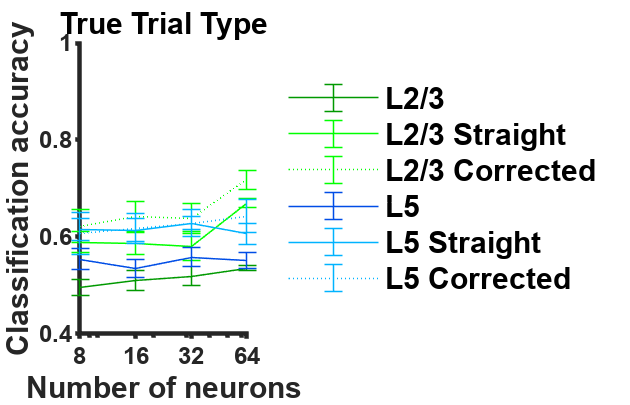

SVGを保存しました: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\rbp4c1336_rbp4c1368_rbp4c1369_clip__blockValue_GLM_push-pull_multi\Decoding_True_Trial_Type_grouped.svg
SVGを保存しました: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\rbp4c1336_rbp4c1368_rbp4c1369_clip__blockValue_GLM_push-pull_multi\Decoding__grouped.svg
SVGを保存しました: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\rbp4c1336_rbp4c1368_rbp4c1369_clip__blockValue_GLM_push-pull_multi\Decoding_Initial_Force_grouped.svg
SVGを保存しました: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\rbp4c1336_rbp4c1368_rbp4c1369_clip__blockValue_GLM_push-pull_multi\Decoding_Final_Choice_grouped.svg


% --- パラメータ定義 ---
n_neurons_list = [8, 16, 32, 64];
label_indices_to_plot = [1, 2, 7, 8]; % プロット対象のラベルインデックス
% label_titles = {'True Trial Type', 'Expected Trial Type','','','','', 'Initial Force', 'Final Choice'};

trial_group_names = {'all_valid', 'straight', 'corrected'};
trial_display_names = {'', 'Straight', 'Corrected'};

if strcmp(block, 'Value')
    % Expected Reward Amount (all_labels_raw の 5番目のカラムに対応)
    label_indices_to_plot(2) = 5; 
    
    label_titles = {'True Trial Type', 'Expected Reward Amount','','','','', 'Initial Force', 'Final Choice'};
    label_titles_map = {'True Trial Type', 'Expected Reward Amount', 'Initial Force', 'Final Choice'};
else
    % デフォルト: Expected Trial Type
    label_titles = {'True Trial Type', 'Expected Trial Type','','','','', 'Initial Force', 'Final Choice'};
    label_titles_map = {'True Trial Type', 'Expected Trial Type', 'Initial Force', 'Final Choice'};
end

% --- メインループ：各ラベルについてプロットを作成 ---
for i_plot = 1:length(label_indices_to_plot)
    
    label_idx = label_indices_to_plot(i_plot);
    current_label_name = label_names{label_idx};
    
    % --- 1. データを集計 ---
    % データを格納するための構造体を初期化
    mean_data = struct();
    sem_data = struct();
    
    for group_name_cell = trial_group_names
        group_name = group_name_cell{:};
        
        % 動物ごとのデータを3次元行列にまとめる
        l23_all_animals = [];
        l5_all_animals = [];
        for i_animal = 1:num_animals
            % results構造体からデータを安全に取得
            if isfield(results(i_animal).L23, group_name) && isfield(results(i_animal).L23.(group_name), current_label_name)
                l23_all_animals = cat(3, l23_all_animals, results(i_animal).L23.(group_name).(current_label_name).accuracy);
                l5_all_animals  = cat(3, l5_all_animals,  results(i_animal).L5.(group_name).(current_label_name).accuracy);
            end
        end
        
        % 平均とSEMを計算
        mean_data.L23.(group_name) = nanmean(l23_all_animals, [2 3]);
        sem_data.L23.(group_name)  = nanstd(l23_all_animals, 0, [2 3]) / sqrt(size(l23_all_animals, 3));
        
        mean_data.L5.(group_name) = nanmean(l5_all_animals, [2 3]);
        sem_data.L5.(group_name)  = nanstd(l5_all_animals, 0, [2 3]) / sqrt(size(l5_all_animals, 3));
    end

    % --- 2. プロット ---
    figure('Position', [10, 10, 280, 180], 'Color', 'w');
    hold on;

    % カラーと線種の定義
    colors_l23 = {[0, 0.6, 0], [0, 1.0, 0], [0, 1.0, 0]}; % 濃い緑, 明るい緑, 明るい緑
    colors_l5  = {[0, 0.3, 0.9], [0, 0.7, 1.0], [0, 0.7, 1.0]}; % 濃い青, 明るい青, 明るい青
    line_styles = {'-', '-', ':'}; % 実線, 実線, 点線
    
    % L2/3のプロット
    for i_group = 1:length(trial_group_names)
        group_name = trial_group_names{i_group};
        errorbar(n_neurons_list, mean_data.L23.(group_name), sem_data.L23.(group_name), ...
            'LineStyle', line_styles{i_group}, 'Color', colors_l23{i_group}, 'LineWidth', 1.5, ...
            'LineWidth', 0.5,'DisplayName', ['L2/3 ' trial_display_names{i_group}]);
    end
    
    % L5のプロット
    for i_group = 1:length(trial_group_names)
        group_name = trial_group_names{i_group};
        errorbar(n_neurons_list, mean_data.L5.(group_name), sem_data.L5.(group_name), ...
            'LineStyle', line_styles{i_group}, 'Color', colors_l5{i_group}, 'LineWidth', 1.5, ...
            'LineWidth', 0.5, 'DisplayName', ['L5 ' trial_display_names{i_group}]);
    end

    % --- 3. SVGスタイルの適用 ---
    ax = gca;
    ax.Box = 'off';
    ax.TickDir = 'out';
    ax.FontSize = 8;
    
    ax.XScale = 'log';
    xlabel('Number of neurons', 'FontSize', 10);
    ylabel('Classification accuracy', 'FontSize', 10);
    
    legend('Location', 'eastoutside', 'FontSize', 10, 'Box', 'off');
    title(label_titles{label_idx}, 'FontSize', 10);
    
    ylim([0.4 1.0]);
    xlim([min(n_neurons_list), max(n_neurons_list)]);
    xticks(n_neurons_list); % X軸の目盛りをリストの値のみに設定

    % --- 4. SVG形式で保存 ---
    safe_title = regexprep(label_titles{label_idx}, '[^\w]', '_');
    filename = fullfile(output_dir, ['Decoding_' safe_title '_grouped.svg']);
    print(gcf, filename, '-dsvg');
    % フィギュアが有効か確認
    fig = gcf; 
    if isvalid(fig)
        % 明示的にフィギュアハンドルを指定して保存
        % '-painters' オプションを付けると、ベクターデータとしてより正確に保存されます
        print(fig, filename, '-dsvg', '-painters');
        
        % 保存が完了したことをコンソールに表示（デバッグ用）
        if exist(filename, 'file')
            fprintf('SVGを保存しました: %s\n', filename);
        else
            warning('SVGの保存に失敗した可能性があります: %s', filename);
        end
    else
        warning('有効なフィギュアが見つかりません。');
    end    
    close(fig);
end

% =========================================================================
% Additional Analysis: Psychometric curve based on resistance difference
% =========================================================================
target_n_cells = [32, 64];
num_conditions = 6;
condition_labels = [-3, -2, -1, 1, 2, 3]; 
% condition_labels mapping:
% -3: Push Easy (ratio=8), -2: Push Med (ratio=4), -1: Push Diff (ratio=2)
%  1: Pull Diff (ratio=0.5), 2: Pull Med (ratio=0.25), 3: Pull Easy (ratio=0.125)

for n_cells = target_n_cells
    
    % Store probabilities for each animal
    % Rows: animals, Columns: conditions (-3, -2, -1, 1, 2, 3)
    pull_prob_L23 = NaN(num_animals, num_conditions);
    pull_prob_L5  = NaN(num_animals, num_conditions);
    
    for i_animal = 1:num_animals
        % Load resistance data for the current session/animal
        % if i_animal <= 8
        %    data_folder = ['E:\Nao_behavior\202506' filesep strjoin(Date(i_animal)) '_' strjoin(Animal(i_animal)) '_' strjoin(Key(i_animal))];
        % elseif i_animal >= 31
        %     data_folder = ['E:\Nao_behavior\202511' filesep strjoin(Date(i_animal)) '_' strjoin(Animal(i_animal)) '_' strjoin(Key(i_animal))];
        % else
        %    data_folder = ['E:\Nao_behavior\202506_Abo' filesep strjoin(Date(i_animal)) '_' strjoin(Animal(i_animal)) '_' strjoin(Key(i_animal))];
        % end
        % data_folder = {[data_parent_dir filesep strjoin(Date(i_animal)) '_' strjoin(Animal(i_animal)) '_' strjoin(Key(i_animal))]};
        % Find existing data folder across candidate parent directories
        subfolder_animal = [strjoin(Date(i_animal)) '_' strjoin(Animal(i_animal)) '_' strjoin(Key(i_animal))];
        search_dirs = cellstr(data_parent_dir);
        data_folder = '';
        
        for d = 1:numel(search_dirs)
            temp_folder = fullfile(search_dirs{d}, subfolder_animal);
            if isfolder(temp_folder)
                data_folder = temp_folder;
                break;
            end
        end
        resistance_table = readtable(fullfile(char(data_folder), 'resistance.csv'));
        pullRes = resistance_table.('pullResistance');
        pushRes = resistance_table.('pushResistance');
        
        % Calculate condition based on resistance ratio (pull/push)
        ratio = pullRes ./ pushRes;
        cond_idx = NaN(size(ratio));
        cond_idx(ratio == 8)    = 1; % Push Easy (-3)
        cond_idx(ratio == 4)    = 2; % Push Med (-2)
        cond_idx(ratio == 2)    = 3; % Push Diff (-1)
        cond_idx(ratio == 0.5)  = 4; % Pull Diff (1)
        cond_idx(ratio == 0.25) = 5; % Pull Med (2)
        cond_idx(ratio == 0.125)= 6; % Pull Easy (3)
        
        % Prepare decoding data (using 'choice_correct' which is column 1)
        labels_raw_full = behavior_cat_dec_data{i_animal}(2:end-1, 1); 
        cond_idx_valid = cond_idx(2:end-1);
        
        valid_mask = ~isnan(labels_raw_full) & ~isnan(cond_idx_valid);
        valid_trials = find(valid_mask);
        
        if isempty(valid_trials) || length(unique(labels_raw_full(valid_trials))) < 2
            continue;
        end
        
        % Neural data (using after_trial_start_act for choice prediction)
        after_start_3d_sess = cat(3, after_trial_start_act{i_animal}{2:end-1});
        
        % Cell indices for L2/3 and L5
        l23_idx = find(pointAreas_data{i_animal} == 1);
        l5_idx  = find(pointAreas_data{i_animal} == 0);
        
        % Cross-validation setup
        cv = cvpartition(labels_raw_full(valid_trials), 'KFold', num_folds);
        
        % --- L2/3 Decoding ---
        if length(l23_idx) >= n_cells
            pred_l23 = NaN(size(labels_raw_full));
            rng(100 + i_animal*10); % Fixed seed for reproducibility
            sub_cells = l23_idx(randperm(length(l23_idx), n_cells));
            
            for i_fold = 1:num_folds
                train_mask = cv.training(i_fold);
                test_mask = cv.test(i_fold);
                
                train_data = after_start_3d_sess(:, sub_cells, valid_trials(train_mask));
                train_X = reshape(train_data, [], sum(train_mask))';
                train_Y = labels_raw_full(valid_trials(train_mask));
                
                test_data = after_start_3d_sess(:, sub_cells, valid_trials(test_mask));
                test_X = reshape(test_data, [], sum(test_mask))';
                
                if length(unique(train_Y)) > 1
                    mdl = fitcecoc(train_X, train_Y, 'Learners', template);
                    pred_l23(valid_trials(test_mask)) = predict(mdl, test_X);
                end
            end
            
            % Calculate pull probability (prediction == 0) per condition
            for c = 1:num_conditions
                idx_c = valid_trials(cond_idx_valid(valid_trials) == c);
                if ~isempty(idx_c)
                    preds_c = pred_l23(idx_c);
                    pull_prob_L23(i_animal, c) = nanmean(preds_c == 0);
                end
            end
        end
        
        % --- L5 Decoding ---
        if length(l5_idx) >= n_cells
            pred_l5 = NaN(size(labels_raw_full));
            rng(500 + i_animal*10); % Fixed seed for reproducibility
            sub_cells = l5_idx(randperm(length(l5_idx), n_cells));
            
            for i_fold = 1:num_folds
                train_mask = cv.training(i_fold);
                test_mask = cv.test(i_fold);
                
                train_data = after_start_3d_sess(:, sub_cells, valid_trials(train_mask));
                train_X = reshape(train_data, [], sum(train_mask))';
                train_Y = labels_raw_full(valid_trials(train_mask));
                
                test_data = after_start_3d_sess(:, sub_cells, valid_trials(test_mask));
                test_X = reshape(test_data, [], sum(test_mask))';
                
                if length(unique(train_Y)) > 1
                    mdl = fitcecoc(train_X, train_Y, 'Learners', template);
                    pred_l5(valid_trials(test_mask)) = predict(mdl, test_X);
                end
            end
            
            % Calculate pull probability (prediction == 0) per condition
            for c = 1:num_conditions
                idx_c = valid_trials(cond_idx_valid(valid_trials) == c);
                if ~isempty(idx_c)
                    preds_c = pred_l5(idx_c);
                    pull_prob_L5(i_animal, c) = nanmean(preds_c == 0);
                end
            end
        end
    end
    
    % --- Plotting Psychometric Curve ---
    mean_L23 = nanmean(pull_prob_L23, 1);
    sem_L23  = nanstd(pull_prob_L23, 0, 1) ./ sqrt(sum(~isnan(pull_prob_L23), 1));
    
    mean_L5 = nanmean(pull_prob_L5, 1);
    sem_L5  = nanstd(pull_prob_L5, 0, 1) ./ sqrt(sum(~isnan(pull_prob_L5), 1));
    
    fig = figure('Position', [100, 100, 300, 250], 'Color', 'w');
    hold on;
    
    % Plot L2/3
    errorbar(condition_labels, mean_L23, sem_L23, '-o', 'Color', [0, 0.6, 0], ...
        'LineWidth', 0.5, 'MarkerSize', 3, 'MarkerFaceColor', [0, 0.6, 0], 'DisplayName', 'L2/3');
    
    % Plot L5
    errorbar(condition_labels, mean_L5, sem_L5, '-o', 'Color', [0, 0.3, 0.9], ...
        'LineWidth', 0.5, 'MarkerSize', 3, 'MarkerFaceColor', [0, 0.3, 0.9], 'DisplayName', 'L5');
    
    % Format axes to match the required paper style (Arial, 7pt, 0.5 line width)
    ax = gca;
    ax.Box = 'off';
    ax.TickDir = 'out';
    ax.FontName = 'Arial';
    ax.FontSize = 7;
    ax.LineWidth = 0.5;
    ax.XColor = 'k';
    ax.YColor = 'k';
    ax.TickLength = [0.02, 0.02]; 
    
    % Custom X-axis labels
    xticks(condition_labels);
    xticklabels({'Push Easy', 'Push Med', 'Push Diff', 'Pull Diff', 'Pull Med', 'Pull Easy'});
    xtickangle(45);
    
    ylim([0 1]);
    yticks([0 0.5 1]);
    
    xlabel('Trial Difficulty', 'FontName', 'Arial', 'FontSize', 7);
    ylabel('Probability of Predicting "Pull"', 'FontName', 'Arial', 'FontSize', 7);
    title(sprintf('Psychometric Curve (%d cells)', n_cells), 'FontName', 'Arial', 'FontSize', 7);
    
    legend('Location', 'southeast', 'Box', 'off', 'FontName', 'Arial', 'FontSize', 7);
    
    % Save as PDF with vector graphics
    if exist('output_dir', 'var')
        filename = fullfile(output_dir, sprintf('Psychometric_Decoding_%dcells.pdf', n_cells));
    else
        filename = sprintf('Psychometric_Decoding_%dcells.pdf', n_cells);
    end
    
    set(fig, 'PaperPositionMode', 'auto');
    print(fig, filename, '-dpdf', '-painters');
    
    close(fig);
end

% --- パラメータ定義 ---
if strcmp(block, 'Value')
    labels_to_decode = [1, 5, 7, 8];
else
    labels_to_decode = [1, 2, 7, 8];
end

% label_titles_map = {'True Trial Type', 'Expected Trial Type', 'Initial Force', 'Final Choice'};
trial_group_names = {'all_valid', 'straight', 'corrected'};
n_neurons_list = [8, 16, 32, 64];

% --- 結果を格納するためのセル配列 ---
stats_results = cell(length(labels_to_decode), 1);

% --- メインループ：各ラベルについて検定を実行 ---
for i_plot = 1:length(labels_to_decode)
    
    label_idx = labels_to_decode(i_plot);
    current_label_name = label_names{label_idx};
    
    % --- このラベルの検定結果を保存するテーブルを初期化 ---
    num_k = length(n_neurons_list);
    p_table = table(n_neurons_list', 'VariableNames', {'NumNeurons'});

    % --- 各ニューロン数ごとにループ ---
    for k = 1:num_k
        
        % 1. 全動物分の配列をNaNで初期化 (サイズ不一致や欠損を防ぐ)
        L23_all       = NaN(num_animals, 1);
        L23_straight  = NaN(num_animals, 1);
        L23_corrected = NaN(num_animals, 1);
        
        L5_all       = NaN(num_animals, 1);
        L5_straight  = NaN(num_animals, 1);
        L5_corrected = NaN(num_animals, 1);

        for i_animal = 1:num_animals
            % --- L2/3 のデータ取得 ---
            % L23の構造体が存在するかチェック
            if isfield(results(i_animal), 'L23') && isfield(results(i_animal).L23, 'all_valid') && isfield(results(i_animal).L23.all_valid, current_label_name)
                % 指定したニューロン数(k)までデータが計算されているかチェック
                if length(results(i_animal).L23.all_valid.(current_label_name).accuracy) >= k
                    L23_all(i_animal)       = results(i_animal).L23.all_valid.(current_label_name).accuracy(k);
                    L23_straight(i_animal)  = results(i_animal).L23.straight.(current_label_name).accuracy(k);
                    L23_corrected(i_animal) = results(i_animal).L23.corrected.(current_label_name).accuracy(k);
                end
            end
            
            % --- L5 のデータ取得 ---
            % L5の構造体が存在するかチェック
            if isfield(results(i_animal), 'L5') && isfield(results(i_animal).L5, 'all_valid') && isfield(results(i_animal).L5.all_valid, current_label_name)
                if length(results(i_animal).L5.all_valid.(current_label_name).accuracy) >= k
                    L5_all(i_animal)       = results(i_animal).L5.all_valid.(current_label_name).accuracy(k);
                    L5_straight(i_animal)  = results(i_animal).L5.straight.(current_label_name).accuracy(k);
                    L5_corrected(i_animal) = results(i_animal).L5.corrected.(current_label_name).accuracy(k);
                end
            end
        end
        
        % --- 2. 層間の比較 (Wilcoxon signed-rank test) ---
        % NaNを除外して有効なペアが1つ以上ある場合のみ検定を実行する（エラー回避）
        if sum(~isnan(L23_all) & ~isnan(L5_all)) > 0
            p_table.P_Layer_all_valid(k)  = signrank(L23_all, L5_all);
        else
            p_table.P_Layer_all_valid(k)  = NaN;
        end
        
        if sum(~isnan(L23_straight) & ~isnan(L5_straight)) > 0
            p_table.P_Layer_straight(k)   = signrank(L23_straight, L5_straight);
        else
            p_table.P_Layer_straight(k)   = NaN;
        end
        
        if sum(~isnan(L23_corrected) & ~isnan(L5_corrected)) > 0
            p_table.P_Layer_corrected(k)  = signrank(L23_corrected, L5_corrected);
        else
            p_table.P_Layer_corrected(k)  = NaN;
        end
        % --- 3. 条件間の比較 (Friedman test + post-hoc) ---
        
        % L2/3
        friedman_matrix_l23 = [L23_all, L23_straight, L23_corrected];
        % a. NaNを含む行(動物)のインデックスを見つける
        rows_with_nan_l23 = any(isnan(friedman_matrix_l23), 2);
        % b. NaNを含まない行だけを抽出して新しい行列を作成
        friedman_matrix_l23_clean = friedman_matrix_l23(~rows_with_nan_l23, :);

        % c. 検定を実行するのに十分なデータがあるかチェック
        if size(friedman_matrix_l23_clean, 1) > 1
            [p, ~, stats] = friedman(friedman_matrix_l23_clean, 1, 'off');
            p_table.P_Cond_L23_main(k) = p;
            if p < 0.05
                c = multcompare(stats, 'CType', 'dunn-sidak', 'Display', 'off');
                p_table.P_L23_all_vs_straight(k)   = c(1,6); % Pair 1-2
                p_table.P_L23_all_vs_corrected(k)  = c(2,6); % Pair 1-3
                p_table.P_L23_straight_vs_corr(k) = c(3,6); % Pair 2-3
            end
        else
            % データ不足で検定不可の場合はNaNを記録
            p_table.P_Cond_L23_main(k) = NaN;
        end

        % L5
        friedman_matrix_l5 = [L5_all, L5_straight, L5_corrected];
        rows_with_nan_l5 = any(isnan(friedman_matrix_l5), 2);
        friedman_matrix_l5_clean = friedman_matrix_l5(~rows_with_nan_l5, :);

        if size(friedman_matrix_l5_clean, 1) > 1
            [p, ~, stats] = friedman(friedman_matrix_l5_clean, 1, 'off');
            p_table.P_Cond_L5_main(k) = p;
            if p < 0.05
                c = multcompare(stats, 'CType', 'dunn-sidak', 'Display', 'off');
                p_table.P_L5_all_vs_straight(k)   = c(1,6);
                p_table.P_L5_all_vs_corrected(k)  = c(2,6);
                p_table.P_L5_straight_vs_corr(k) = c(3,6);
            end
        else
            p_table.P_Cond_L5_main(k) = NaN;
        end
    end
    
    % --- 4. 各検定セットに対して多重比較補正 (FDR) ---
    % -----------------------------------------------------------------
    % FDR補正 (Benjamini-Hochberg法)
    % -----------------------------------------------------------------
    test_types = p_table.Properties.VariableNames(2:end);
    for i_test = 1:length(test_types)
        test_name = test_types{i_test};
        if contains(test_name, 'main'), continue; end % main effect は対象外
        
        raw_p = p_table.(test_name);
        valid_idx = ~isnan(raw_p);
        
        if any(valid_idx)
            raw_p_valid = raw_p(valid_idx);
            
            % --- B-H法によるFDR (q-value) の手動計算 ---
            % p値が少ない場合でも確実に計算でき、クラッシュしません
            m = length(raw_p_valid);
            [sorted_p, sort_idx] = sort(raw_p_valid(:)); % 昇順ソート
            
            % q = p * (m / k)
            fdr_sorted = sorted_p .* (m ./ (1:m)');
            
            % 単調増加を保証する (Step-up procedure)
            for j = m-1:-1:1
                fdr_sorted(j) = min(fdr_sorted(j), fdr_sorted(j+1));
            end
            fdr_sorted = min(fdr_sorted, 1); % 最大値は1に制限
            
            % 元の順序に戻す
            fdr_p_valid = zeros(m, 1);
            fdr_p_valid(sort_idx) = fdr_sorted;
            % ---------------------------------------------------------
            
            fdr_p_all = NaN(num_k, 1);
            fdr_p_all(valid_idx) = fdr_p_valid;
            p_table.(['FDR_' test_name]) = fdr_p_all;
        else
            p_table.(['FDR_' test_name]) = NaN(num_k, 1);
        end
    end
    
    % --- 5. 結果を保存 ---
    stats_results{i_plot} = p_table;
    
    % 結果を表示
    fprintf('\n\n==================================================\n');
    fprintf('--- Statistical Results for: %s ---\n', label_titles_map{i_plot});
    fprintf('==================================================\n');
    disp(p_table);
end

--- Statistical Results for: True Trial Type ---


    NumNeurons    P_Layer_all_valid    P_Layer_straight    P_Layer_corrected    P_Cond_L23_main    P_L23_all_vs_straight    P_L23_all_vs_corrected    P_L23_straight_vs_corr    P_Cond_L5_main    P_L5_all_vs_straight    P_L5_all_vs_corrected    P_L5_straight_vs_corr    FDR_P_Layer_all_valid    FDR_P_Layer_straight    FDR_P_Layer_corrected    FDR_P_L23_all_vs_straight    FDR_P_L23_all_vs_corrected    FDR_P_L23_straight_vs_corr    FDR_P_L5_all_vs_straight    FDR_P_L5_all_vs_corrected    FDR_P_L5_straight_vs_corr
    __________    _________________    ________________    ___________

--- Statistical Results for: Expected Reward Amount ---


    NumNeurons    P_Layer_all_valid    P_Layer_straight    P_Layer_corrected    P_Cond_L23_main    P_Cond_L5_main    P_L5_all_vs_straight    P_L5_all_vs_corrected    P_L5_straight_vs_corr    P_L23_all_vs_straight    P_L23_all_vs_corrected    P_L23_straight_vs_corr    FDR_P_Layer_all_valid    FDR_P_Layer_straight    FDR_P_Layer_corrected    FDR_P_L5_all_vs_straight    FDR_P_L5_all_vs_corrected    FDR_P_L5_straight_vs_corr    FDR_P_L23_all_vs_straight    FDR_P_L23_all_vs_corrected    FDR_P_L23_straight_vs_corr
    __________    _________________    ________________    ___________

--- Statistical Results for: Initial Force ---


    NumNeurons    P_Layer_all_valid    P_Layer_straight    P_Layer_corrected    P_Cond_L23_main    P_Cond_L5_main    P_L5_all_vs_straight    P_L5_all_vs_corrected    P_L5_straight_vs_corr    FDR_P_Layer_all_valid    FDR_P_Layer_straight    FDR_P_Layer_corrected    FDR_P_L5_all_vs_straight    FDR_P_L5_all_vs_corrected    FDR_P_L5_straight_vs_corr
    __________    _________________    ________________    _________________    _______________    ______________    ____________________    _____________________    _____________________    _____________________    ___

--- Statistical Results for: Final Choice ---


    NumNeurons    P_Layer_all_valid    P_Layer_straight    P_Layer_corrected    P_Cond_L23_main    P_Cond_L5_main    P_L5_all_vs_straight    P_L5_all_vs_corrected    P_L5_straight_vs_corr    FDR_P_Layer_all_valid    FDR_P_Layer_straight    FDR_P_Layer_corrected    FDR_P_L5_all_vs_straight    FDR_P_L5_all_vs_corrected    FDR_P_L5_straight_vs_corr
    __________    _________________    ________________    _________________    _______________    ______________    ____________________    _____________________    _____________________    _____________________    ___


% --- テキスト保存の設定 ---
txt_filename = fullfile(output_dir, 'Decoding_Statistical_Results.txt');
fid = fopen(txt_filename, 'w');

if fid == -1
    error('ファイルを開くことができませんでした: %s', txt_filename);
end

% ヘッダー情報の書き込み
fprintf(fid, '==================================================\n');
fprintf(fid, 'STATISTICAL ANALYSIS REPORT\n');
fprintf(fid, 'Date: %s\n', datestr(now));
fprintf(fid, '==================================================\n\n');

for i_res = 1:length(stats_results)
    current_p_table = stats_results{i_res};
    label_title = label_titles_map{i_res};
    
    % ラベルごとのタイトル書き込み
    fprintf(fid, '--------------------------------------------------\n');
    fprintf(fid, 'Label: %s\n', label_title);
    fprintf(fid, '--------------------------------------------------\n');
    
    % テーブルのヘッダー（列名）を書き込み
    col_names = current_p_table.Properties.VariableNames;
    fprintf(fid, '%s\n', strjoin(col_names, '\t'));
    
    % 各行のデータを書き込み
    for row = 1:height(current_p_table)
        row_data = current_p_table{row, :};
        % 数値データをタブ区切りで文字列化
        row_str = strjoin(arrayfun(@(x) sprintf('%.4f', x), row_data, 'UniformOutput', false), '\t');
        fprintf(fid, '%s\n', row_str);
    end
    fprintf(fid, '\n'); % ラベル間に空行を入れる
end

fclose(fid);
fprintf('統計結果を保存しました: %s\n', txt_filename);

統計結果を保存しました: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\rbp4c1336_rbp4c1368_rbp4c1369_clip__blockValue_GLM_push-pull_multi\Decoding_Statistical_Results.txt


% =========================================================================
% 切り替わり前後のデコーディング性能プロットとPDF保存
% =========================================================================

if ~isempty(all_reversal_acc_L23) && ~isempty(all_reversal_acc_L5)
    
    % 各相対試行位置における全切り替わり点の平均値と標準誤差を計算
    mean_L23 = mean(all_reversal_acc_L23, 1, 'omitnan');
    mean_L5  = mean(all_reversal_acc_L5, 1, 'omitnan');
    
    sem_L23  = std(all_reversal_acc_L23, 0, 1, 'omitnan') ./ sqrt(sum(~isnan(all_reversal_acc_L23), 1));
    sem_L5   = std(all_reversal_acc_L5, 0, 1, 'omitnan') ./ sqrt(sum(~isnan(all_reversal_acc_L5), 1));
    
    % --- プロット設定 ---
    % サイズは参照コードに合わせ調整
    fig = figure('Position', [10, 10, 400, 180], 'Color', 'w');
    hold on;
    
    % 参照コードのメインカラー（all_valid に相当する濃い色）を採用
    color_l23_main = [0, 0.6, 0];       % 濃い緑
    color_l5_main  = [0, 0.3, 0.9];     % 濃い青
    
    % L2/3のプロット（シェーディングで標準誤差を表示）
    fill([relative_trials, fliplr(relative_trials)], [mean_L23 + sem_L23, fliplr(mean_L23 - sem_L23)], ...
         color_l23_main, 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    hL23 = plot(relative_trials, mean_L23, 'Color', color_l23_main, 'LineWidth', 1.5, 'DisplayName', 'L2/3 (32 cells)');
    
    % L5のプロット
    % ★ HandleVisibility を off にして影の凡例を非表示に
    fill([relative_trials, fliplr(relative_trials)], [mean_L5 + sem_L5, fliplr(mean_L5 - sem_L5)], ...
         color_l5_main, 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    hL5 = plot(relative_trials, mean_L5, 'Color', color_l5_main, 'LineWidth', 1.5, 'DisplayName', 'L5 (32 cells)');
    
    % 切り替わり線（x=0）のガイドライン
    line([0 0], [0 1], 'Color', [0.5 0.5 0.5], 'LineStyle', '--', 'LineWidth', 0.5, 'HandleVisibility', 'off');
    
    % --- SVGスタイル・軸の適用 ---
    ax = gca;
    ax.Box = 'off';
    ax.TickDir = 'out';
    ax.FontSize = 8;
    
    set(ax, 'XLim', [min(relative_trials), max(relative_trials)], 'YLim', [0.4 1.0]);
    set(ax, 'XTick', -window_trials:10:window_trials);
    
    xlabel('Trials from block switch', 'FontSize', 10);
    ylabel('Decoding accuracy', 'FontSize', 10);
    
    legend('Location', 'eastoutside', 'FontSize', 10, 'Box', 'off');
    title('Decoding Performance around Block Switch', 'FontSize', 10);
    
    % --- 指定の出力ディレクトリ（output_dir）へPDF形式で保存 ---
    % ※ 論文用の統一スタイル（Arialフォント・レイアウト維持）のため、ベクトル保存可能なPDF形式で出力します。
    filename = fullfile(output_dir, 'Decoding_Performance_Block_Switch.pdf');
    
    if isvalid(fig)
        set(fig, 'PaperPositionMode', 'auto');
        print(fig, filename, '-dpdf', '-painters');
        
        if exist(filename, 'file')
            fprintf('PDFを保存しました: %s\n', filename);
        else
            warning('PDFの保存に失敗した可能性があります: %s', filename);
        end
    else
        warning('有効なフィギュアが見つかりません。');
    end    
    close(fig);
else
    warning('有効なブロック切り替わり試行が見つかりませんでした。');
end

PDFを保存しました: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\rbp4c1336_rbp4c1368_rbp4c1369_clip__blockValue_GLM_push-pull_multi\Decoding_Performance_Block_Switch.pdf



% =========================================================================
% 行動ブロック切り替わり前後の行動正解率 & ブロック一貫性選択確率プロット
% =========================================================================

if ~isempty(all_reversal_behav_acc) && ~isempty(all_reversal_behav_cons)
    
    % 平均値と標準誤差（SEM）の計算
    mean_behav_acc  = mean(all_reversal_behav_acc, 1, 'omitnan');
    mean_behav_cons = mean(all_reversal_behav_cons, 1, 'omitnan');
    
    sem_behav_acc   = std(all_reversal_behav_acc, 0, 1, 'omitnan') ./ sqrt(sum(~isnan(all_reversal_behav_acc), 1));
    sem_behav_cons  = std(all_reversal_behav_cons, 0, 1, 'omitnan') ./ sqrt(sum(~isnan(all_reversal_behav_cons), 1));
    
    % --- プロット設定 ---
    fig = figure('Position', [10, 10, 400, 180], 'Color', 'w');
    hold on;
    
    % オレンジと紫のカラー定義
    color_acc  = [0.9, 0.4, 0.0];  % オレンジ (行動正解率)
    color_cons = [0.5, 0.1, 0.6];  % 紫 (ブロック一貫選択確率)
    
    % 1. 行動正解率のプロット（影の凡例は非表示）
    fill([relative_trials, fliplr(relative_trials)], [mean_behav_acc + sem_behav_acc, fliplr(mean_behav_acc - sem_behav_acc)], ...
         color_acc, 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    hAcc = plot(relative_trials, mean_behav_acc, 'Color', color_acc, 'LineWidth', 1.5, 'DisplayName', 'Accuracy');
    
    % 2. ブロック一貫選択確率のプロット（影の凡例は非表示）
    fill([relative_trials, fliplr(relative_trials)], [mean_behav_cons + sem_behav_cons, fliplr(mean_behav_cons - sem_behav_cons)], ...
         color_cons, 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    hCons = plot(relative_trials, mean_behav_cons, 'Color', color_cons, 'LineWidth', 1.5, 'DisplayName', 'Block-Consistent');
    
    % 切り替わり線（x=0）のガイドライン
    line([0 0], [0 1], 'Color', [0.5 0.5 0.5], 'LineStyle', '--', 'LineWidth', 0.5, 'HandleVisibility', 'off');
    
    % --- 軸・スタイルの適用 ---
    ax = gca;
    ax.Box = 'off';
    ax.TickDir = 'out';
    ax.FontSize = 8;
    
    set(ax, 'XLim', [min(relative_trials), max(relative_trials)], 'YLim', [0.4 1.0]);
    set(ax, 'XTick', -window_trials:10:window_trials);
    
    xlabel('Trials from block switch', 'FontSize', 10);
    ylabel('Probability', 'FontSize', 10);
    
    legend('Location', 'eastoutside', 'FontSize', 10, 'Box', 'off');
    title('Behavior Metrics around Block Switch', 'FontSize', 10);
    
    % --- 指定の出力ディレクトリ（output_dir）へPDF形式で保存 ---
    filename = fullfile(output_dir, 'Behavior_Metrics_Block_Switch.pdf');
    
    if isvalid(fig)
        set(fig, 'PaperPositionMode', 'auto');
        print(fig, filename, '-dpdf', '-painters');
        fprintf('行動指標のPDFを保存しました: %s\n', filename);
    else
        warning('有効なフィギュアが見つかりません。');
    end    
    close(fig);
else
    warning('有効な行動切り替わりデータが見つかりませんでした。');
end

行動指標のPDFを保存しました: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\rbp4c1336_rbp4c1368_rbp4c1369_clip__blockValue_GLM_push-pull_multi\Behavior_Metrics_Block_Switch.pdf


% =========================================================================
% クロスデコーディング結果の集計・プロット・統計検定（Expected Trial Type のみ）
% =========================================================================

% ★ label_idx = 2 (Expected Trial Type) のみを対象に設定
if strcmp(block, 'Value')
    target_label_idx = 5; % 5: reward_pred
    label_title_target = 'Expected Reward Amount';
else
    target_label_idx = 2; % 2: choice_pred
    label_title_target = 'Expected Trial Type';
end

current_label_name = label_names{target_label_idx};
n_neurons_list = [8, 16, 32, 64];

% --- 1. データを集計 ---
l23_cross_animals = [];
l5_cross_animals  = [];

for i_animal = 1:num_animals
    if isfield(results_cross(i_animal), 'L23') && isfield(results_cross(i_animal).L23, current_label_name)
        l23_cross_animals = [l23_cross_animals; results_cross(i_animal).L23.(current_label_name).accuracy];
        l5_cross_animals  = [l5_cross_animals;  results_cross(i_animal).L5.(current_label_name).accuracy];
    end
end

mean_l23 = nanmean(l23_cross_animals, 1);
sem_l23  = nanstd(l23_cross_animals, 0, 1) ./ sqrt(sum(~isnan(l23_cross_animals), 1));

mean_l5  = nanmean(l5_cross_animals, 1);
sem_l5   = nanstd(l5_cross_animals, 0, 1) ./ sqrt(sum(~isnan(l5_cross_animals), 1));

% --- 2. プロット作成 ---
fig = figure('Position', [10, 10, 240, 180], 'Color', 'w');
hold on;

% 指定されたカラー定義スタイルを反映
color_l23 = [0, 0.6, 0];       % 濃い緑
color_l5  = [0, 0.3, 0.9];     % 濃い青

errorbar(n_neurons_list, mean_l23, sem_l23, 'LineStyle', '-', 'Color', color_l23, ...
         'LineWidth', 0.5, 'DisplayName', 'L2/3');
errorbar(n_neurons_list, mean_l5, sem_l5, 'LineStyle', '-', 'Color', color_l5, ...
         'LineWidth', 0.5, 'DisplayName', 'L5');
     
ax = gca;
ax.Box = 'off';
ax.TickDir = 'out';
ax.FontSize = 8;
ax.XScale = 'log';

xlabel('Number of neurons', 'FontSize', 10);
ylabel('Classification accuracy', 'FontSize', 10);
legend('Location', 'eastoutside', 'FontSize', 10, 'Box', 'off');
title([label_title_target], 'FontSize', 10);

ylim([0.4 1.0]);
xlim([min(n_neurons_list), max(n_neurons_list)]);
xticks(n_neurons_list);

% SVG保存
safe_title = regexprep(label_title_target, '[^\w]', '_');
filename_svg = fullfile(output_dir, ['Decoding_' safe_title '_cross_block.svg']);
print(fig, filename_svg, '-dsvg', '-painters');
close(fig);

% --- 3. 統計検定の実行 ---
num_k = length(n_neurons_list);
p_table = table(n_neurons_list', 'VariableNames', {'NumNeurons'});

for k = 1:num_k
    L23_k = l23_cross_animals(:, k);
    L5_k  = l5_cross_animals(:, k);
    
    % 層間比較 (Wilcoxon signed-rank test)
    if sum(~isnan(L23_k) & ~isnan(L5_k)) > 0
        p_table.P_Layer_Cross(k) = signrank(L23_k, L5_k);
    else
        p_table.P_Layer_Cross(k) = NaN;
    end
end

% 多重比較補正 (FDR補正)
raw_p = p_table.P_Layer_Cross;
valid_idx = ~isnan(raw_p);
if any(valid_idx)
    raw_p_valid = raw_p(valid_idx);
    m = length(raw_p_valid);
    [sorted_p, sort_idx] = sort(raw_p_valid(:));
    fdr_sorted = sorted_p .* (m ./ (1:m)');
    for j = m-1:-1:1
        fdr_sorted(j) = min(fdr_sorted(j), fdr_sorted(j+1));
    end
    fdr_sorted = min(fdr_sorted, 1);
    fdr_p_valid = zeros(m, 1);
    fdr_p_valid(sort_idx) = fdr_sorted;
    
    fdr_p_all = NaN(num_k, 1);
    fdr_p_all(valid_idx) = fdr_p_valid;
    p_table.FDR_P_Layer_Cross = fdr_p_all;
else
    p_table.FDR_P_Layer_Cross = NaN(num_k, 1);
end

% --- 4. 統計結果のテキスト保存 ---
txt_filename = fullfile(output_dir, 'Decoding_Cross_Block_Statistical_Results.txt');
fid = fopen(txt_filename, 'w');
if fid ~= -1
    fprintf(fid, '==================================================\n');
    fprintf(fid, 'CROSS-BLOCK DECODING STATISTICAL ANALYSIS REPORT\n');
    fprintf(fid, 'Date: %s\n', datestr(now));
    fprintf(fid, '==================================================\n\n');
    
    fprintf(fid, '--------------------------------------------------\n');
    fprintf(fid, 'Label: %s\n', label_title_target);
    fprintf(fid, '--------------------------------------------------\n');
    
    col_names = p_table.Properties.VariableNames;
    fprintf(fid, '%s\n', strjoin(col_names, '\t'));
    
    for row = 1:height(p_table)
        row_data = p_table{row, :};
        row_str = strjoin(arrayfun(@(x) sprintf('%.4f', x), row_data, 'UniformOutput', false), '\t');
        fprintf(fid, '%s\n', row_str);
    end
    fclose(fid);
    fprintf('クロスブロック統計結果を保存しました: %s\n', txt_filename);
end

クロスブロック統計結果を保存しました: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260824_value\rbp4c1336_rbp4c1368_rbp4c1369_clip__blockValue_GLM_push-pull_multi\Decoding_Cross_Block_Statistical_Results.txt


%% =========================================================================
% GLM-HMM 状態 (State) を予測するデコーディング解析 (トライアルタイプ別)
% =========================================================================
if GLM_HMM
    fprintf('\n==================================================\n');
    fprintf('--- Decoding GLM-HMM States from Neural Activity ---\n');
    fprintf('==================================================\n');
    
    % --- 1. GLM-HMMデータの読み込み ---
    glm_hmm_file = fullfile(strjoin(data_folders(1)), 'glm_hmm_states_all_sessions.csv');
    if ~isfile(glm_hmm_file)
        warning('glm_hmm_states_all_sessions.csv が見つかりません。パスを確認してください。');
    else
        glm_hmm_data = readtable(glm_hmm_file);
        unique_glm_sessions = unique(glm_hmm_data.Session_ID);
    
        % 結果保存用構造体とパラメータ
        results_state_dec = struct();
        windows_to_decode = {'before_force', 'after_force'};
        window_titles = {'Before Initial Force', 'After Initial Force'};
        
        trial_group_names = {'all_valid', 'straight', 'corrected'};
        trial_display_names = {'All Valid', 'Straight', 'Corrected'};
    
        % --- 2. 各動物に対するデコーディング実行 ---
        for i_animal = 1:num_animals
            fprintf('\n--- Processing Animal %d of %d (State Decoding) ---\n', i_animal, num_animals);
            
            % GLM-HMMのデータを取得
            session_glm_data = glm_hmm_data(glm_hmm_data.Session_ID == unique_glm_sessions(i_animal), :);
            
            % 神経データ・行動データで解析対象となるトライアルのインデックス (通常 2 ~ end-1)
            num_total_trials = length(before_initial_force_act{i_animal});
            target_trials = 2:(num_total_trials - 1);
            
            % ラベル配列をNaNで初期化 (欠損トライアルはNaNになる)
            labels_raw = NaN(length(target_trials), 1);
            
            % Trial_ID をキーにしてGLM-HMMのStateをマッピング
            for i_t = 1:height(session_glm_data)
                t_id = session_glm_data.Trial_ID(i_t);
                idx_in_target = find(target_trials == t_id);
                
                if ~isempty(idx_in_target)
                    labels_raw(idx_in_target) = session_glm_data.Max_State(i_t);
                end
            end
            
            nan_mask = isnan(labels_raw);
            
            % 試行グループのマスクを作成
            all_labels_raw = behavior_cat_dec_data{i_animal}(2:end-1, :);
            straight_trials_mask = (all_labels_raw(:,7) == all_labels_raw(:,8));
            corrected_trials_mask = (all_labels_raw(:,7) ~= all_labels_raw(:,8));
            trial_group_masks = {true(size(all_labels_raw,1),1), straight_trials_mask, corrected_trials_mask};
            
            % 神経データの取得 (3次元テンソル化)
            before_force_3d = cat(3, before_initial_force_act{i_animal}{2:end-1});
            after_force_3d  = cat(3, after_initial_force_act{i_animal}{2:end-1});
            
            % ニューロンの層情報を取得
            pointAreas = pointAreas_data{i_animal};
            l23_idx_all = find(pointAreas == 1);
            l5_idx_all  = find(pointAreas == 0);
            
            % ウィンドウごとのデコーディング
            for w = 1:2
                win_name = windows_to_decode{w};
                fprintf('  Window: %s\n', win_name);
                
                if w == 1
                    data_3d = before_force_3d;
                else
                    data_3d = after_force_3d;
                end
                
                % トライアルグループごとのデコーディング
                for i_group = 1:length(trial_group_names)
                    group_name = trial_group_names{i_group};
                    
                    % マスクの結合 (条件マスク & NaNでない)
                    final_trial_mask = trial_group_masks{i_group} & ~nan_mask;
                    
                    labels_final = labels_raw(final_trial_mask);
                    data_final = data_3d(:, :, final_trial_mask);
                    
                    % クラス数（状態数）が2以上あるか確認
                    if isempty(labels_final) || length(unique(labels_final)) < 2
                        fprintf('    Group: %s -> Skipping, not enough valid trials or states to decode.\n', group_name);
                        continue;
                    end
                    
                    % 乱数シードの設定 (再現性のため)
                    rng_seed_offset = w*10 + i_animal*100 + i_group*1000;
                    
                    % run_decoding 関数を呼び出し
                    [acc_l23, ~] = run_decoding(data_final, labels_final, l23_idx_all, n_neurons_list, template, num_folds, rng_seed_offset);
                    [acc_l5,  ~] = run_decoding(data_final, labels_final, l5_idx_all,  n_neurons_list, template, num_folds, rng_seed_offset + 500);
                    
                    % 結果の保存
                    results_state_dec(i_animal).L23.(win_name).(group_name).accuracy = acc_l23;
                    results_state_dec(i_animal).L5.(win_name).(group_name).accuracy  = acc_l5;
                end
            end
        end
    
        % --- 3. データ集計、プロット、および統計検定 ---
        stats_results_state_dec = cell(length(windows_to_decode), 1);
        
        % カラーと線種の定義
        colors_l23 = {[0, 0.6, 0], [0, 1.0, 0], [0, 1.0, 0]}; % 濃い緑, 明るい緑, 明るい緑
        colors_l5  = {[0, 0.3, 0.9], [0, 0.7, 1.0], [0, 0.7, 1.0]}; % 濃い青, 明るい青, 明るい青
        line_styles = {'-', '-', ':'}; % 実線, 実線, 点線
    
        for w = 1:length(windows_to_decode)
            win_name = windows_to_decode{w};
            
            mean_data = struct();
            sem_data = struct();
            all_l23 = struct();
            all_l5 = struct();
            
            % グループごとのデータ集計
            for i_group = 1:length(trial_group_names)
                group_name = trial_group_names{i_group};
                
            num_k = length(n_neurons_list);
            l23_all_animals = NaN(num_k, 1, num_animals);
            l5_all_animals  = NaN(num_k, 1, num_animals);
                
                for i_animal = 1:num_animals
                    if isfield(results_state_dec(i_animal).L23, win_name) && isfield(results_state_dec(i_animal).L23.(win_name), group_name)
                        l23_all_animals(:, 1, i_animal) = results_state_dec(i_animal).L23.(win_name).(group_name).accuracy;
                        l5_all_animals(:, 1, i_animal)  = results_state_dec(i_animal).L5.(win_name).(group_name).accuracy;
                    end
                end
                
                if ~isempty(l23_all_animals)
                    mean_data.L23.(group_name) = nanmean(l23_all_animals, [2 3]);
                    n_valid_l23 = sum(~isnan(l23_all_animals), 3);
                    sem_data.L23.(group_name)  = nanstd(l23_all_animals, 0, 3) ./ sqrt(n_valid_l23);
                end
                if any(~isnan(l5_all_animals(:)))
                    mean_data.L5.(group_name) = nanmean(l5_all_animals, 3);
                    n_valid_l5 = sum(~isnan(l5_all_animals), 3);
                    sem_data.L5.(group_name)  = nanstd(l5_all_animals, 0, 3) ./ sqrt(n_valid_l5);
                end
                
                % 統計検定用に全動物のデータを保持
                all_l23.(group_name) = l23_all_animals;
                all_l5.(group_name)  = l5_all_animals;
            end
            
            % -----------------------------------------------------------------
            % プロットの作成
            % -----------------------------------------------------------------
            figure('Position', [10, 10, 280, 180], 'Color', 'w');
            hold on;
            
            % L2/3
            for i_group = 1:length(trial_group_names)
                group_name = trial_group_names{i_group};
                if isfield(mean_data.L23, group_name)
                    errorbar(n_neurons_list, mean_data.L23.(group_name), sem_data.L23.(group_name), ...
                        'LineStyle', line_styles{i_group}, 'Color', colors_l23{i_group}, ...
                        'LineWidth', 1.5, 'DisplayName', ['L2/3 ' trial_display_names{i_group}]);
                end
            end
            
            % L5
            for i_group = 1:length(trial_group_names)
                group_name = trial_group_names{i_group};
                if isfield(mean_data.L5, group_name)
                    errorbar(n_neurons_list, mean_data.L5.(group_name), sem_data.L5.(group_name), ...
                        'LineStyle', line_styles{i_group}, 'Color', colors_l5{i_group}, ...
                        'LineWidth', 1.5, 'DisplayName', ['L5 ' trial_display_names{i_group}]);
                end
            end
            
            ax = gca; ax.Box = 'off'; ax.TickDir = 'out'; ax.FontSize = 8;
            ax.XScale = 'log';
            xlabel('Number of neurons', 'FontSize', 10);
            ylabel('State Decoding Accuracy', 'FontSize', 10);
            legend('Location', 'eastoutside', 'FontSize', 8, 'Box', 'off');
            title(window_titles{w}, 'FontSize', 10);
            
            ylim([0.3 1.0]); 
            xlim([min(n_neurons_list), max(n_neurons_list)]);
            xticks(n_neurons_list);
            
            % SVG形式で保存
            filename_svg = fullfile(output_dir, ['Decoding_GLMHMM_State_' win_name '_grouped.svg']);
            fig = gcf;
            if isvalid(fig)
                print(fig, filename_svg, '-dsvg', '-painters');
                fprintf('SVGを保存しました: %s\n', filename_svg);
            end
            close(fig);
            
            % -----------------------------------------------------------------
            % 統計検定 (Layer間、Condition間)
            % -----------------------------------------------------------------
            num_k = length(n_neurons_list);
            p_table = table(n_neurons_list', 'VariableNames', {'NumNeurons'});
            
            % 必要な変数が存在するか確認（データ不足への対応）
            has_all = isfield(all_l23, 'all_valid') && isfield(all_l5, 'all_valid');
            has_str = isfield(all_l23, 'straight') && isfield(all_l5, 'straight');
            has_cor = isfield(all_l23, 'corrected') && isfield(all_l5, 'corrected');
    
            for k = 1:num_k
                % 1. 各ニューロン数のデータを抽出・Wilcoxon検定 (確実に列ベクトル化する)
                if has_all
                    L23_all_val = all_l23.all_valid(k, 1, :); L23_all_val = L23_all_val(:);
                    L5_all_val  = all_l5.all_valid(k, 1, :);  L5_all_val  = L5_all_val(:);
                    if sum(~isnan(L23_all_val) & ~isnan(L5_all_val)) >= 3
                        p_table.P_Layer_all_valid(k) = signrank(L23_all_val, L5_all_val);
                    else, p_table.P_Layer_all_valid(k) = NaN; end
                end
                
                if has_str
                    L23_str_val = all_l23.straight(k, 1, :); L23_str_val = L23_str_val(:);
                    L5_str_val  = all_l5.straight(k, 1, :);  L5_str_val  = L5_str_val(:);
                    if sum(~isnan(L23_str_val) & ~isnan(L5_str_val)) >= 3
                        p_table.P_Layer_straight(k) = signrank(L23_str_val, L5_str_val);
                    else, p_table.P_Layer_straight(k) = NaN; end
                end
                
                if has_cor
                    L23_cor_val = all_l23.corrected(k, 1, :); L23_cor_val = L23_cor_val(:);
                    L5_cor_val  = all_l5.corrected(k, 1, :);  L5_cor_val  = L5_cor_val(:);
                    if sum(~isnan(L23_cor_val) & ~isnan(L5_cor_val)) >= 3
                        p_table.P_Layer_corrected(k) = signrank(L23_cor_val, L5_cor_val);
                    else, p_table.P_Layer_corrected(k) = NaN; end
                end
                
                % 2. 条件間の比較 (Friedman test + post-hoc)
                if has_all && has_str && has_cor
                    % L2/3
                    friedman_matrix_l23 = [L23_all_val, L23_str_val, L23_cor_val];
                    rows_with_nan_l23 = any(isnan(friedman_matrix_l23), 2);
                    friedman_matrix_l23_clean = friedman_matrix_l23(~rows_with_nan_l23, :);
                    if size(friedman_matrix_l23_clean, 1) > 1
                        [p, ~, stats] = friedman(friedman_matrix_l23_clean, 1, 'off');
                        p_table.P_Cond_L23_main(k) = p;
                        if p < 0.05
                            c = multcompare(stats, 'CType', 'dunn-sidak', 'Display', 'off');
                            if k == 1
                                p_table.P_L23_all_vs_straight = NaN(num_k, 1);
                                p_table.P_L23_all_vs_corrected = NaN(num_k, 1);
                                p_table.P_L23_straight_vs_corr = NaN(num_k, 1);
                            end
                            p_table.P_L23_all_vs_straight(k)  = c(1,6);
                            p_table.P_L23_all_vs_corrected(k) = c(2,6);
                            p_table.P_L23_straight_vs_corr(k) = c(3,6);
                        end
                    end
                    
                    % L5
                    friedman_matrix_l5 = [L5_all_val, L5_str_val, L5_cor_val];
                    rows_with_nan_l5 = any(isnan(friedman_matrix_l5), 2);
                    friedman_matrix_l5_clean = friedman_matrix_l5(~rows_with_nan_l5, :);
                    if size(friedman_matrix_l5_clean, 1) > 1
                        [p, ~, stats] = friedman(friedman_matrix_l5_clean, 1, 'off');
                        p_table.P_Cond_L5_main(k) = p;
                        if p < 0.05
                            c = multcompare(stats, 'CType', 'dunn-sidak', 'Display', 'off');
                            if k == 1
                                p_table.P_L5_all_vs_straight = NaN(num_k, 1);
                                p_table.P_L5_all_vs_corrected = NaN(num_k, 1);
                                p_table.P_L5_straight_vs_corr = NaN(num_k, 1);
                            end
                            p_table.P_L5_all_vs_straight(k)  = c(1,6);
                            p_table.P_L5_all_vs_corrected(k) = c(2,6);
                            p_table.P_L5_straight_vs_corr(k) = c(3,6);
                        end
                    end
                end
            end
            
            % FDR補正
            test_types = p_table.Properties.VariableNames(2:end);
            for i_test = 1:length(test_types)
                test_name = test_types{i_test};
                if contains(test_name, 'main'), continue; end
                
                raw_p = p_table.(test_name);
                valid_idx = ~isnan(raw_p);
                if any(valid_idx)
                    raw_p_valid = raw_p(valid_idx);
                    raw_p_valid(raw_p_valid == 0) = realmin;
                    try
                        fdr_p = mafdr(raw_p_valid', 'Lambda', 0.001:0.01:0.99);
                        fdr_p_all = NaN(num_k, 1);
                        fdr_p_all(valid_idx) = fdr_p';
                        p_table.(['FDR_' test_name]) = fdr_p_all;
                    catch
                        p_table.(['FDR_' test_name]) = raw_p;
                    end
                else
                    p_table.(['FDR_' test_name]) = NaN(num_k, 1);
                end
            end
            
            stats_results_state_dec{w} = p_table;
            fprintf('\n--- State Decoding Stats: %s ---\n', window_titles{w});
            disp(p_table);
        end
    
        % --- 4. 結果のテキスト保存 ---
        txt_filename = fullfile(output_dir, 'Decoding_GLMHMM_State_Results_Grouped.txt');
        fid = fopen(txt_filename, 'w');
        if fid ~= -1
            fprintf(fid, '==================================================\n');
            fprintf(fid, 'GLM-HMM STATE DECODING ANALYSIS (Grouped by Trial Type)\n');
            fprintf(fid, 'Date: %s\n', datestr(now));
            fprintf(fid, '==================================================\n\n');
            
            for w = 1:length(windows_to_decode)
                if isempty(stats_results_state_dec{w}), continue; end
                
                fprintf(fid, '--------------------------------------------------\n');
                fprintf(fid, 'Window: %s\n', window_titles{w});
                fprintf(fid, '--------------------------------------------------\n');
                
                curr_table = stats_results_state_dec{w};
                col_names = curr_table.Properties.VariableNames;
                fprintf(fid, '%s\n', strjoin(col_names, '\t'));
                
                for row = 1:height(curr_table)
                    row_data = curr_table{row, :};
                    % 数値データを適切に文字列化してタブ区切りで書き込み
                    row_str = [];
                    for c = 1:length(row_data)
                        val = row_data(c);
                        if isnumeric(val)
                            row_str = [row_str, sprintf('%.4f\t', val)];
                        else
                            row_str = [row_str, sprintf('%s\t', val)];
                        end
                    end
                    fprintf(fid, '%s\n', strtrim(row_str));
                end
                fprintf(fid, '\n');
            end
            fclose(fid);
            fprintf('状態予測の統計結果を保存しました: %s\n', txt_filename);
        else
            warning('ファイルを開くことができませんでした: %s', txt_filename);
        end
    end
end

% %% =========================================================================
% % GLM-HMM 状態 (State) ごとのデコーディング精度のプロットと統計的検定
% % =========================================================================
% 
% if GLM_HMM
%     fprintf('\n==================================================\n');
%     fprintf('--- GLM-HMM States Decoding Analysis ---\n');
%     fprintf('==================================================\n');
% 
%     % --- 1. GLM-HMMのステートグループを動的に取得 ---
%     state_group_names = {};
%     if exist('results', 'var') && ~isempty(results)
%         fields = fieldnames(results(1).L23);
%         for i = 1:length(fields)
%             if startsWith(fields{i}, 'state_')
%                 state_group_names{end+1} = fields{i};
%             end
%         end
%     end
% 
%     if isempty(state_group_names)
%         fprintf('GLM-HMMの状態 (state_*) が結果に見つかりません。解析をスキップします。\n');
%     else
%         % 結果保存用セル配列
%         stats_results_states = cell(length(label_indices_to_plot), 1);
% 
%         % --- メインループ：各ラベルについて処理 ---
%         for i_plot = 1:length(label_indices_to_plot)
%             label_idx = label_indices_to_plot(i_plot);
%             current_label_name = label_names{label_idx};
% 
%             % ----------------------------------------------------
%             % 2. プロット用データの集計
%             % ----------------------------------------------------
%             mean_data_state = struct();
%             sem_data_state  = struct();
% 
%             for i_state = 1:length(state_group_names)
%                 group_name = state_group_names{i_state};
% 
%                 l23_all_animals = [];
%                 l5_all_animals  = [];
%                 for i_animal = 1:num_animals
%                     if isfield(results(i_animal).L23, group_name) && isfield(results(i_animal).L23.(group_name), current_label_name)
%                         l23_all_animals = cat(3, l23_all_animals, results(i_animal).L23.(group_name).(current_label_name).accuracy);
%                         l5_all_animals  = cat(3, l5_all_animals,  results(i_animal).L5.(group_name).(current_label_name).accuracy);
%                     end
%                 end
% 
%                 if isempty(l23_all_animals) || isempty(l5_all_animals)
%                     continue;
%                 end
% 
%                 % 平均とSEMの計算
%                 mean_data_state.L23.(group_name) = nanmean(l23_all_animals, [2 3]);
%                 sem_data_state.L23.(group_name)  = nanstd(l23_all_animals, 0, [2 3]) / sqrt(size(l23_all_animals, 3));
% 
%                 mean_data_state.L5.(group_name) = nanmean(l5_all_animals, [2 3]);
%                 sem_data_state.L5.(group_name)  = nanstd(l5_all_animals, 0, [2 3]) / sqrt(size(l5_all_animals, 3));
%             end
% 
%             % ----------------------------------------------------
%             % 3. SVGプロットの作成
%             % ----------------------------------------------------
%             figure('Position', [10, 10, 350, 200], 'Color', 'w');
%             hold on;
% 
%             % Stateの数に合わせて色と線種を生成 (L2/3: 緑系, L5: 青系)
%             num_states = length(state_group_names);
%             colors_l23_states = [zeros(num_states,1), linspace(0.4, 1.0, num_states)', zeros(num_states,1)];
%             colors_l5_states  = [zeros(num_states,1), linspace(0.3, 0.8, num_states)', linspace(0.6, 1.0, num_states)'];
%             line_styles_states = repmat({'-', '--', ':', '-.'}, 1, ceil(num_states/4));
% 
%             for i_state = 1:num_states
%                 group_name = state_group_names{i_state};
%                 if ~isfield(mean_data_state.L23, group_name), continue; end
% 
%                 display_name = strrep(group_name, '_', ' '); % 'state_0' -> 'state 0'
% 
%                 % L2/3 の描画
%                 errorbar(n_neurons_list, mean_data_state.L23.(group_name), sem_data_state.L23.(group_name), ...
%                     'LineStyle', line_styles_states{i_state}, 'Color', colors_l23_states(i_state,:), ...
%                     'LineWidth', 1.0, 'DisplayName', ['L2/3 ' display_name]);
% 
%                 % L5 の描画
%                 errorbar(n_neurons_list, mean_data_state.L5.(group_name), sem_data_state.L5.(group_name), ...
%                     'LineStyle', line_styles_states{i_state}, 'Color', colors_l5_states(i_state,:), ...
%                     'LineWidth', 1.0, 'DisplayName', ['L5 ' display_name]);
%             end
% 
%             ax = gca; ax.Box = 'off'; ax.TickDir = 'out'; ax.FontSize = 8;
%             ax.XScale = 'log';
%             xlabel('Number of neurons', 'FontSize', 10);
%             ylabel('Classification accuracy', 'FontSize', 10);
%             legend('Location', 'eastoutside', 'FontSize', 8, 'Box', 'off');
%             title([label_titles{label_idx} ' (GLM-HMM States)'], 'FontSize', 10);
% 
%             ylim([0.4 1.0]);
%             xlim([min(n_neurons_list), max(n_neurons_list)]);
%             xticks(n_neurons_list);
% 
%             % SVG保存
%             safe_title = regexprep(label_titles{label_idx}, '[^\w]', '_');
%             filename_state = fullfile(output_dir, ['Decoding_' safe_title '_states.svg']);
%             fig_state = gcf;
%             if isvalid(fig_state)
%                 print(fig_state, filename_state, '-dsvg', '-painters');
%                 fprintf('Stateプロットを保存しました: %s\n', filename_state);
%             end
%             close(fig_state);
% 
%             % ----------------------------------------------------
%             % 4. 統計検定 (L2/3 vs L5 within each State)
%             % ----------------------------------------------------
%             num_k = length(n_neurons_list);
% 
%             % テーブルの列名を動的に作成
%             var_names = {'NumNeurons'};
%             for i_state = 1:num_states
%                 var_names{end+1} = ['P_Layer_' state_group_names{i_state}];
%             end
% 
%             p_table_state = table('Size', [num_k, length(var_names)], ...
%                 'VariableTypes', repmat({'double'}, 1, length(var_names)), ...
%                 'VariableNames', var_names);
%             p_table_state.NumNeurons = n_neurons_list';
% 
%             for k = 1:num_k
%                 for i_state = 1:num_states
%                     group_name = state_group_names{i_state};
%                     L23_state_vals = [];
%                     L5_state_vals  = [];
% 
%                     for i_animal = 1:num_animals
%                         if isfield(results(i_animal).L23, group_name) && isfield(results(i_animal).L23.(group_name), current_label_name)
%                             L23_state_vals = [L23_state_vals; results(i_animal).L23.(group_name).(current_label_name).accuracy(k)];
%                             L5_state_vals  = [L5_state_vals;  results(i_animal).L5.(group_name).(current_label_name).accuracy(k)];
%                         end
%                     end
% 
%                     % L2/3 vs L5 (Wilcoxon signed-rank test)
%                     if length(L23_state_vals) >= 3 && length(L5_state_vals) >= 3
%                         p_table_state{k, ['P_Layer_' group_name]} = signrank(L23_state_vals, L5_state_vals);
%                     else
%                         p_table_state{k, ['P_Layer_' group_name]} = NaN;
%                     end
%                 end
%             end
% 
%             % FDR補正 (mafdr)
%             test_types = p_table_state.Properties.VariableNames(2:end);
%             for i_test = 1:length(test_types)
%                 test_name = test_types{i_test};
%                 raw_p_values = p_table_state.(test_name);
%                 valid_idx = ~isnan(raw_p_values);
% 
%                 if any(valid_idx)
%                     raw_p_valid = raw_p_values(valid_idx);
%                     raw_p_valid(raw_p_valid == 0) = realmin;
%                     lambda_range = 0.001:0.01:0.99;
%                     try
%                         fdr_p_valid = mafdr(raw_p_valid', 'Lambda', lambda_range);
%                         fdr_p_values = NaN(size(raw_p_values));
%                         fdr_p_values(valid_idx) = fdr_p_valid';
%                         p_table_state.(['FDR_' test_name]) = fdr_p_values;
%                     catch
%                         p_table_state.(['FDR_' test_name]) = raw_p_values; % パッケージ不在等でエラー時は生のp値を保持
%                     end
%                 else
%                     p_table_state.(['FDR_' test_name]) = NaN(size(raw_p_values));
%                 end
%             end
% 
%             % セルに保存してコンソールに表示
%             stats_results_states{i_plot} = p_table_state;
%             fprintf('\n--- State Statistical Results for: %s ---\n', label_titles{label_idx});
%             disp(p_table_state);
%         end
% 
%         % ----------------------------------------------------
%         % 5. 結果をテキストファイルに書き出し
%         % ----------------------------------------------------
%         txt_filename_states = fullfile(output_dir, 'Decoding_Statistical_Results_States.txt');
%         fid_states = fopen(txt_filename_states, 'w');
% 
%         if fid_states ~= -1
%             fprintf(fid_states, '==================================================\n');
%             fprintf(fid_states, 'GLM-HMM STATES STATISTICAL ANALYSIS REPORT\n');
%             fprintf(fid_states, 'Date: %s\n', datestr(now));
%             fprintf(fid_states, '==================================================\n\n');
% 
%             for i_res = 1:length(stats_results_states)
%                 current_p_table = stats_results_states{i_res};
%                 if isempty(current_p_table), continue; end
% 
%                 label_idx = label_indices_to_plot(i_res);
%                 label_title = label_titles{label_idx};
% 
%                 fprintf(fid_states, '--------------------------------------------------\n');
%                 fprintf(fid_states, 'Label: %s\n', label_title);
%                 fprintf(fid_states, '--------------------------------------------------\n');
% 
%                 col_names = current_p_table.Properties.VariableNames;
%                 fprintf(fid_states, '%s\n', strjoin(col_names, '\t'));
% 
%                 for row = 1:height(current_p_table)
%                     row_data = current_p_table{row, :};
%                     row_str = strjoin(arrayfun(@(x) sprintf('%.4f', x), row_data, 'UniformOutput', false), '\t');
%                     fprintf(fid_states, '%s\n', row_str);
%                 end
%                 fprintf(fid_states, '\n');
%             end
%             fclose(fid_states);
%             fprintf('Stateごとの統計結果を保存しました: %s\n', txt_filename_states);
%         else
%             warning('ファイルを開くことができませんでした: %s', txt_filename_states);
%         end
%     end
% end

% 横軸のニューロン数
n_neurons = [8, 16, 32, 64]; %, 128];
num_animals = length(Animal);
num_cells = length(n_neurons);

% カテゴリ名
label_titles = {'True Trial Type', 'Expected Trial Type', 'Resistance Error', ...
                'True Reward', 'Expected Reward', 'Reward Error', 'Initial Force', 'Final Choice'};

num_categories = length(label_titles);

% 各カテゴリについてループ
for c = 1:num_categories
    % 初期化
    l23_before_all = [];
    l23_after_all  = [];
    l5_before_all  = [];
    l5_after_all   = [];

    % Animalごとに結合（カテゴリc）
    for i = 1:num_animals
        l23_before_all = cat(3, l23_before_all, l23_acc_before{c,i});
        l23_after_all  = cat(3, l23_after_all,  l23_acc_after{c,i});
        l5_before_all  = cat(3, l5_before_all,  l5_acc_before{c,i});
        l5_after_all   = cat(3, l5_after_all,   l5_acc_after{c,i});
    end

    % 平均と標準誤差を計算（細胞数ごと）
    mean_l23_before = nanmean(l23_before_all, [2 3]);
    mean_l23_after  = nanmean(l23_after_all,  [2 3]);
    mean_l5_before  = nanmean(l5_before_all,  [2 3]);
    mean_l5_after   = nanmean(l5_after_all,   [2 3]);

    sem_l23_before = nanstd(l23_before_all, 0, [2 3]) / sqrt(num_animals);
    sem_l23_after  = nanstd(l23_after_all,  0, [2 3]) / sqrt(num_animals);
    sem_l5_before  = nanstd(l5_before_all,  0, [2 3]) / sqrt(num_animals);
    sem_l5_after   = nanstd(l5_after_all,   0, [2 3]) / sqrt(num_animals);

    % プロット
    figure; hold on;
    errorbar(n_neurons, mean_l23_before, sem_l23_before, '-o', 'Color', [0 .6 0], 'LineWidth', 1.5, 'DisplayName', 'L2/3 - Before');
    errorbar(n_neurons, mean_l23_after,  sem_l23_after,  '-o', 'Color', [0 .8 0], 'LineWidth', 1.5, 'DisplayName', 'L2/3 - After');
    errorbar(n_neurons, mean_l5_before,  sem_l5_before,  '-o', 'Color', [0 0.3 0.9], 'LineWidth', 1.5, 'DisplayName', 'L5 - Before');
    errorbar(n_neurons, mean_l5_after,   sem_l5_after,   '-o', 'Color', [0 0.5 1.0], 'LineWidth', 1.5, 'DisplayName', 'L5 - After');

    set(gca, 'XScale', 'log');
    xlabel('Number of neurons');
    ylabel('Classification accuracy');
    legend('Location', 'southeast');
    title(['Decoding accuracy: ' label_titles{c}]);
    ylim([0.5 1]);
    % xlim([8 105]);

    % 保存
    safe_title = regexprep(label_titles{c}, '[^\w]', '_');
    filename = fullfile(output_dir, ['Decoding_' safe_title '_before_after.png']);
    saveas(gcf, filename);
end

Undefined variable 'l23_acc_before'.

% Plot for Cosyne2026 abstract
% カテゴリ名
n_neurons_list = [8, 16, 32, 64]; %, 128]; 
label_titles = {'True Trial Type', 'Expected Trial Type', 'Resistance Error', ...
                'True Reward', 'Expected Reward', 'Reward Error', 'Initial Force', 'Final Choice'};
num_categories = length(label_titles);

% ★ 検定結果を保存するためのテーブルを初期化
p_values_table = table();
p_values_table.Num_of_Cells = n_neurons_list';
p_values_table.P_value_Before = NaN(length(n_neurons_list), 1);
p_values_table.P_value_After = NaN(length(n_neurons_list), 1);

% 各カテゴリについてループ
for c = 1:num_categories
    % --- データ集計 (この部分は変更なし) ---
    l23_before_all = [];
    l23_after_all  = [];
    l5_before_all  = [];
    l5_after_all   = [];

    for i = 1:num_animals
        l23_before_all = cat(3, l23_before_all, l23_acc_before{c,i});
        l23_after_all  = cat(3, l23_after_all,  l23_acc_after{c,i});
        l5_before_all  = cat(3, l5_before_all,  l5_acc_before{c,i});
        l5_after_all   = cat(3, l5_after_all,   l5_acc_after{c,i});
    end

    mean_l23_before = nanmean(l23_before_all, [2 3]);
    mean_l23_after  = nanmean(l23_after_all,  [2 3]);
    mean_l5_before  = nanmean(l5_before_all,  [2 3]);
    mean_l5_after   = nanmean(l5_after_all,   [2 3]);

    sem_l23_before = nanstd(l23_before_all, 0, [2 3]) / sqrt(num_animals);
    sem_l23_after  = nanstd(l23_after_all,  0, [2 3]) / sqrt(num_animals);
    sem_l5_before  = nanstd(l5_before_all,  0, [2 3]) / sqrt(num_animals);
    sem_l5_after   = nanstd(l5_after_all,   0, [2 3]) / sqrt(num_animals);

    % --- 各ニューロン数ごとに層間の差を検定 ---
    for k = 1:length(n_neurons_list)

        % Before条件のデータを抽出 (k番目のニューロン数に対応)
        l23_before_k = squeeze(l23_before_all(k, :, :));
        l5_before_k  = squeeze(l5_before_all(k, :, :));

        % NaNを除去して検定を実行
        valid_idx = ~isnan(l23_before_k) & ~isnan(l5_before_k);
        if sum(valid_idx) > 1 % データが2つ以上ないと検定できない
             p_before = signrank(l23_before_k(valid_idx), l5_before_k(valid_idx));
             p_values_table.P_value_Before(k) = p_before;
        end

        % After条件のデータを抽出
        l23_after_k = squeeze(l23_after_all(k, :, :));
        l5_after_k  = squeeze(l5_after_all(k, :, :));

        valid_idx = ~isnan(l23_after_k) & ~isnan(l5_after_k);
        if sum(valid_idx) > 1
            p_after = signrank(l23_after_k(valid_idx), l5_after_k(valid_idx));
            p_values_table.P_value_After(k) = p_after;
        end
        % --- p値の補正 ---
        num_tests = height(p_values_table); % 検定の回数 (5)
        % --- ボンフェローニ補正 ---
        p_values_table.Bonferroni_Before = p_values_table.P_value_Before * num_tests;
        p_values_table.Bonferroni_After  = p_values_table.P_value_After  * num_tests;
        % 補正後のp値が1を超えた場合は1にクリップする
        p_values_table.Bonferroni_Before(p_values_table.Bonferroni_Before > 1) = 1;
        p_values_table.Bonferroni_After(p_values_table.Bonferroni_After > 1) = 1;
        % % --- FDRによる補正 (mafdr関数を使用) ---
        % [fdr_p_before] = mafdr(p_values_table.P_value_Before);
        % [fdr_p_after]  = mafdr(p_values_table.P_value_After);
        % p_values_table.FDR_Before = fdr_p_before;
        % p_values_table.FDR_After  = fdr_p_after;
    end

    % 結果の表示
    disp(['=== Stats for: ' label_titles{c} ' ===']);
    disp(p_values_table);    

    % ★★★★★★★★★★★★★★★ ここからプロット部分を修正 ★★★★★★★★★★★★★★★

    % --- プロット ---
    figure('Position', [10, 10, 300, 190], 'Color', 'w');
    hold on;

    errorbar(n_neurons, mean_l23_before, sem_l23_before, '-', 'Color', [0 .6 0], 'LineWidth', 0.5, 'DisplayName', 'L2/3 - Before');
    errorbar(n_neurons, mean_l23_after,  sem_l23_after,  '-', 'Color', [0 .8 0], 'LineWidth', 0.5, 'DisplayName', 'L2/3 - After');
    errorbar(n_neurons, mean_l5_before,  sem_l5_before,  '-', 'Color', [0 0.3 0.9], 'LineWidth', 0.5, 'DisplayName', 'L5 - Before');
    errorbar(n_neurons, mean_l5_after,   sem_l5_after,   '-', 'Color', [0 0.5 1.0], 'LineWidth', 0.5, 'DisplayName', 'L5 - After');

    ax = gca;
    ax.Box = 'off';
    ax.TickDir = 'out';
    ax.FontSize = 7;

    ax.XScale = 'log';
    xlabel('Number of neurons', 'FontSize', 8);
    ylabel('Classification accuracy', 'FontSize', 8);

    % ★ 凡例をプロット領域の右外側に配置
    % 'Location', 'eastoutside' は右側中央の外に配置します
    % 'FontSize' と 'Box' の設定はそのまま維持
    lgd = legend('Location', 'eastoutside', 'FontSize', 7, 'Box', 'off'); % フォントサイズを7に統一
    % lgd.Layout.Tile = 'east'; % タイトルレイアウトを使用している場合に、凡例を独立したタイルとして配置

    title([label_titles{c}], 'FontSize', 8);

    ylim([0.5 0.9]); %([0.5 1]);
    xlim([min(n_neurons)-1, max(n_neurons)+10]);

    safe_title = regexprep(label_titles{c}, '[^\w]', '_');
    filename = fullfile(output_dir, ['Decoding_' safe_title '_before_after.svg']);
    % ★ グラフのサイズに合わせて凡例の位置を調整するために、printの前にgetframeを追加
    % print関数は現在のFigureの状態をそのまま保存するので、
    % 凡例の位置調整を確実にするためgetframeを入れてレンダリングを促す
    drawnow; % 描画を強制
    print(gcf, filename, '-dsvg', '-r300');

    close(gcf);
end

% 横軸のニューロン数
n_neurons = [8, 16, 32, 64, 128];
num_animals = length(Animal);
num_cells = length(n_neurons);

% カテゴリ名
label_titles = {'True Resistance', 'Expected Resistance', 'Resistance Error', ...
                'True Reward', 'Expected Reward', 'Reward Error', 'First Choice', 'Final Choice'};

num_categories = length(label_titles);

% 各カテゴリについてループ
for c = 1:num_categories
    % 初期化
    l23_before_all = [];
    l23_after_all  = [];
    l5_before_all  = [];
    l5_after_all   = [];

    % Animalごとに結合（カテゴリc）
    for i = 1:num_animals
        l23_before_all = cat(3, l23_before_all, f1_l23_before{c,i});
        l23_after_all  = cat(3, l23_after_all,  f1_l23_after{c,i});
        l5_before_all  = cat(3, l5_before_all,  f1_l5_before{c,i});
        l5_after_all   = cat(3, l5_after_all,   f1_l5_after{c,i});
    end

    % 平均と標準誤差を計算（細胞数ごと）
    mean_l23_before = nanmean(l23_before_all, [2 3]);
    mean_l23_after  = nanmean(l23_after_all,  [2 3]);
    mean_l5_before  = nanmean(l5_before_all,  [2 3]);
    mean_l5_after   = nanmean(l5_after_all,   [2 3]);

    sem_l23_before = nanstd(l23_before_all, 0, [2 3]) / sqrt(num_animals);
    sem_l23_after  = nanstd(l23_after_all,  0, [2 3]) / sqrt(num_animals);
    sem_l5_before  = nanstd(l5_before_all,  0, [2 3]) / sqrt(num_animals);
    sem_l5_after   = nanstd(l5_after_all,   0, [2 3]) / sqrt(num_animals);

    % プロット
    figure; hold on;
    errorbar(n_neurons, mean_l23_before, sem_l23_before, '-o', 'Color', [0 .6 0], 'LineWidth', 1.5, 'DisplayName', 'L2/3 - Before');
    errorbar(n_neurons, mean_l23_after,  sem_l23_after,  '-o', 'Color', [0 .8 0], 'LineWidth', 1.5, 'DisplayName', 'L2/3 - After');
    errorbar(n_neurons, mean_l5_before,  sem_l5_before,  '-o', 'Color', [0 0.3 0.9], 'LineWidth', 1.5, 'DisplayName', 'L5 - Before');
    errorbar(n_neurons, mean_l5_after,   sem_l5_after,   '-o', 'Color', [0 0.5 1.0], 'LineWidth', 1.5, 'DisplayName', 'L5 - After');

    set(gca, 'XScale', 'log');
    xlabel('Number of neurons');
    ylabel('Macro-F1 score');
    legend('Location', 'southeast');
    title(['Decoding F1 score: ' label_titles{c}]);
    ylim([0 1]);

    % 保存
    safe_title = regexprep(label_titles{c}, '[^\w]', '_');
    filename = fullfile(output_dir, ['F1score_' safe_title '_before_after.png']);
    saveas(gcf, filename);
end

% ニューロン数と対象インデックス
n_neurons = [8, 16, 32, 64, 128];
idx_32cell = find(n_neurons == 16);

% カテゴリインデックス（Expected Resistance と True Resistance）
idx_expected = find(strcmp(label_titles, 'Expected Reward'));
idx_true     = find(strcmp(label_titles, 'True Reward'));

% 精度の抽出
% acc_l23_expected = squeeze(l23_acc_before{idx_expected, 1:num_animals});
% acc_l5_expected  = squeeze(l5_acc_before{idx_expected, 1:num_animals});
% acc_l23_true     = squeeze(l23_acc_after{idx_true, 1:num_animals});
% acc_l5_true      = squeeze(l5_acc_after{idx_true, 1:num_animals});

% 各セッションから32細胞のデータを抽出
get_32cell = @(cell_array) cellfun(@(x) x(idx_32cell), cell_array(:));

l23_expected_32 = get_32cell(l23_acc_before(idx_expected, 1:num_animals));
l5_expected_32  = get_32cell(l5_acc_before(idx_expected, 1:num_animals));
l23_true_32     = get_32cell(l23_acc_after(idx_true, 1:num_animals));
l5_true_32      = get_32cell(l5_acc_after(idx_true, 1:num_animals));

% 棒グラフ描画用にまとめる
group_names = {'Expected L2/3', 'Expected L5', 'True L2/3', 'True L5'};
data = [l23_expected_32, l5_expected_32, l23_true_32, l5_true_32];

% 平均とSEM
means = nanmean(data, 1);
sems  = nanstd(data, 0, 1) ./ sqrt(sum(~isnan(data), 1));

% プロット
figure;
bar(means, 'FaceColor', 'flat');
hold on;
errorbar(1:4, means, sems, 'k.', 'LineWidth', 1.5);
set(gca, 'XTickLabel', group_names, 'XTick', 1:4);
ylabel('Classification Accuracy');
title('L2/3 vs L5: Expected vs True Resistance (32 neurons)');
ylim([0.5 1]);
grid on;

% Welch t-test (unequal variance)
[p1, ~] = ttest2(l23_expected_32(~isnan(l23_expected_32)), l5_expected_32(~isnan(l5_expected_32)), 'Vartype','unequal');
[p2, ~] = ttest2(l23_true_32(~isnan(l23_true_32)),     l5_true_32(~isnan(l5_true_32)),     'Vartype','unequal');

% 結果表示
fprintf('Welch t-test (Expected Reward): L2/3 vs L5: p = %.4f\n', p1);
fprintf('Welch t-test (True Reward):     L2/3 vs L5: p = %.4f\n', p2);

% ニューロン数と対象インデックス
n_neurons = [8, 16, 32, 64, 128];
idx_32cell = find(n_neurons == 16);

% カテゴリインデックス（Expected Resistance と True Resistance）
idx_expected = find(strcmp(label_titles, 'Expected Resistance'));
idx_true     = find(strcmp(label_titles, 'True Resistance'));

% 精度の抽出
% acc_l23_expected = squeeze(l23_acc_before{idx_expected, 1:num_animals});
% acc_l5_expected  = squeeze(l5_acc_before{idx_expected, 1:num_animals});
% acc_l23_true     = squeeze(l23_acc_after{idx_true, 1:num_animals});
% acc_l5_true      = squeeze(l5_acc_after{idx_true, 1:num_animals});

% 各セッションから32細胞のデータを抽出
get_32cell = @(cell_array) cellfun(@(x) x(idx_32cell), cell_array(:));

l23_expected_32 = get_32cell(l23_acc_before(idx_expected, 1:num_animals));
l5_expected_32  = get_32cell(l5_acc_before(idx_expected, 1:num_animals));
l23_true_32     = get_32cell(l23_acc_after(idx_true, 1:num_animals));
l5_true_32      = get_32cell(l5_acc_after(idx_true, 1:num_animals));


% 棒グラフ描画用にまとめる
group_names = {'Expected L2/3', 'Expected L5', 'True L2/3', 'True L5'};
data = [l23_expected_32, l5_expected_32, l23_true_32, l5_true_32];

% 平均とSEM
means = nanmean(data, 1);
sems  = nanstd(data, 0, 1) ./ sqrt(sum(~isnan(data), 1));

% プロット
figure;
bar(means, 'FaceColor', 'flat');
hold on;
errorbar(1:4, means, sems, 'k.', 'LineWidth', 1.5);
set(gca, 'XTickLabel', group_names, 'XTick', 1:4);
ylabel('Classification Accuracy');
title('L2/3 vs L5: Expected vs True Resistance (32 neurons)');
ylim([0.5 1]);
grid on;

% Welch t-test (unequal variance)
[p1, ~] = ttest2(l23_expected_32(~isnan(l23_expected_32)), l5_expected_32(~isnan(l5_expected_32)), 'Vartype','unequal');
[p2, ~] = ttest2(l23_true_32(~isnan(l23_true_32)),     l5_true_32(~isnan(l5_true_32)),     'Vartype','unequal');

% 結果表示
fprintf('Welch t-test (Expected Resistance): L2/3 vs L5: p = %.4f\n', p1);
fprintf('Welch t-test (True Resistance):     L2/3 vs L5: p = %.4f\n', p2);

[h1, p1, ci1, stats1] = ttest2(l23_expected_32(~isnan(l23_expected_32)), l5_expected_32(~isnan(l5_expected_32)), 'Vartype','unequal')
[h2, p2, ci2, stats2] = ttest2(l23_true_32(~isnan(l23_true_32)),     l5_true_32(~isnan(l5_true_32)),     'Vartype','unequal')

% input_types = {'Before', 'After'};
% data_types = {'l23_acc_before', 'l5_acc_before'; 'l23_acc_after', 'l5_acc_after'};
% titles = {'Before trial start', 'After trial start'};

% カテゴリインデックスとデータ抽出 (ご提示のコード)
idx_expected = find(strcmp(label_titles, 'Expected Resistance'));
idx_true     = find(strcmp(label_titles, 'True Resistance'));

% l23_expected = l23_acc_after(idx_expected, 1:num_animals);
% l5_expected  = l5_acc_after(idx_expected, 1:num_animals);
% l23_true     = l23_acc_before(idx_true, 1:num_animals);
% l5_true      = l5_acc_before(idx_true, 1:num_animals);

l23_expected = l23_acc_before(idx_expected, 1:num_animals);
l5_expected  = l5_acc_before(idx_expected, 1:num_animals);
l23_true     = l23_acc_after(idx_true, 1:num_animals);
l5_true      = l5_acc_after(idx_true, 1:num_animals);

% 検定で使用するニューロン数のラベル
neuron_labels = {'8cells', '16cells', '32cells', '64cells', '128cells'};

% --- 'Expected Resistance' の検定 (計画的比較) ---
fprintf('\n\n--- Planned Comparisons: Expected Resistance (Wilcoxon signed-rank) ---\n');
stats_table_expected = perform_paired_tests(l23_expected, l5_expected, neuron_labels);

disp(stats_table_expected);

% --- 'True Resistance' の検定 (計画的比較) ---
fprintf('\n\n--- Planned Comparisons: True Resistance (Wilcoxon signed-rank) ---\n');
stats_table_true = perform_paired_tests(l23_true, l5_true, neuron_labels);

disp(stats_table_true);

size(l23_acc_before)

% % Categorical decoding analysis
% % 1つ前の抵抗を記録
% resistance_pred = [NaN; resistance(1:end-1)];
% 
% % 抵抗値が前と違う場所を1とする
% resistance_error = [0; resistance(2:end) ~= resistance(1:end-1)];
% 
% reward_amount = []
% for i = 1:length(resistance)
%     temp_trial      = trial(i);
%     temp_resistance = resistance(i);
%     if temp_trial <= length(resistance)/2 && temp_resistance > 8
%         reward_amount(end+1) = 1;
%     elseif temp_trial <= length(resistance)/2 && temp_resistance == 8
%         reward_amount(end+1) = 5;
%     elseif temp_trial > length(resistance)/2 && temp_resistance > 8
%         reward_amount(end+1) = 5;
%     elseif temp_trial > length(resistance)/2 && temp_resistance == 8
%         reward_amount(end+1) = 1;
%     end
% end
% 
% block_size = 25;
% num_blocks = floor(length(reward_amount) / block_size);
% reward_pred = zeros(length(reward_amount), 1);  % 予測配列
% 
% for i = 1:num_blocks
%     idx_start = (i-1)*block_size + 1;
%     idx_end = i*block_size;
%     block = reward_amount(idx_start:idx_end);
% 
%     % 1と5の出現数を数える
%     n1 = sum(block == 1);
%     n5 = sum(block == 5);
% 
%     % 多い方の値を予測に使う（同数なら1とする）
%     if n5 > n1
%         pred_val = 5;
%     else
%         pred_val = 1;
%     end
% 
%     reward_pred(idx_start:idx_end) = pred_val;
% end
% 
% % 予測と実際の不一致をエラーとして 1 にする
% reward_error = double(reward_pred ~= reward_amount);

% for i = 1:length(titles)
%     if i == 3
%         continue;
%     end
%     i_l23_R = l23_Rs(:,:,i+2);
%     i_l5_R  = l5_Rs(:,:,i+2);
%     data    = [transpose(i_l23_R); transpose(i_l5_R)];
% %     data = randn(20,5);
%     factor1 = [repmat({'L23'},10,5); repmat({'L5'},10,5)];
%     factor2 = repmat({'8cells','16cells','32cells','64cells','128cells'}, 20,1);
%     [p, tbl, stats] = anovan(data(:), {factor1(:),factor2(:)}, 'varnames', {'layer','num_of_cells'}, 'display', 'off'); %, 'model', 'interaction', 'display', 'off');
%     [c, m, h, nms]  = multcompare(stats, 'dimension', [1,2], 'display', 'off'); %, 'ctype', 'hsd', 'display', 'off');
% 
%     disp(titles{i});
%     disp('2-way ANOVA:');
%     disp(tbl);
%     disp('Tukey multi comparison:');
%     tbl2 = array2table(c,"VariableNames",["Group1","Group2","Lower Limit","A-B","Upper Limit","P-value"]);
%     tbl2.("Group1")=nms(tbl2.("Group1"));
%     tbl2.("Group2")=nms(tbl2.("Group2"));
%     disp(tbl2);
% %     disp([nms num2cell(c)]);
%     ANOVA_filename = [output_dir Date '_'  Animal  '_' titles{i} '_ANOVA.csv'];
%     writecell(tbl, ANOVA_filename);
%     Tukey_filename = [output_dir Date '_'  Animal  '_' titles{i} '_Tukey.csv'];
% %     resultTable = array2table([nms num2cell(c)]);
%     writetable(tbl2, Tukey_filename);
% end

% For test of GLM code

% X = behavior_data_train; %randn(100,20);
% weights = [.4;.2;.3];
% mu = exp(X(:,[5 10 15])*weights + 1);
% y =poissrnd(mu);
% [B,FitInfo] = lassoglm(X,y,'poisson','CV',5);
% idxLamdaMinDeviance =FitInfo.IndexMinDeviance;
% mincoefs = find(B(:,idxLambdaMinDeviance))
% idxLambda1SE = FitInfo.Index1SE;
% min1coefs = find(B(:,idxLambda1SE))
% B0 = FitInfo.Intercept(idxLambdaMinDeviance);
% y_pred = glmval([B0; B(:,idxLambdaMinDeviance)],X,'log');
% B0_ = FitInfo.Intercept(idxLambda1SE);
% y_pred_ = glmval([B0; B(:,idxLambda1SE)],X,'log');
%     SStot = sum((y - mean(y)).^2);
%     SSres = sum((y - y_pred_).^2);
% %     SSres = sum((processed_neural_activity_data_test(:,i_cell) - processed_neural_activity_data_pred{i_cell,1}).^2);
%     R2 = 1 - SSres/SStot
%     figure
%     plot(1:size(X,1),y,1:size(X,1),y_pred,1:size(X,1),y_pred_);
%     title(['Generalized linear model Explained variation' num2str(R2)]);
% %     xlabel('time');
% %     ylabel('normalized neural activity');
%     % ylim([-0.2 1.2]);
%     % xlim([0 max(p_time_temp_transformed)]);
%     legend({'Actual','Predicted MinDeviance', 'Predicted SE'},'Location','northwest');

% =========================================================================
% 多重共線性の診断：行動変数(X_data)の相関行列の計算と可視化
% =========================================================================

% 確認したいセッション（例：セッション1）の学習データを取得
check_session = 1; 
X_check = behavior_data_train{check_session};

% NaNを除外して相関行列(Pearson)を計算
fprintf('Calculating correlation matrix for Session %d...\n', check_session);
R_matrix = corr(X_check, 'Rows', 'pairwise');

% --- プロットの作成 ---
figure('Color', 'w', 'Position', [100, 100, 800, 700], 'Name', 'Correlation Matrix');

% heatmap関数より高速で柔軟な imagesc を使用
imagesc(R_matrix);

% カラーマップとスケールの設定
colormap(jet);      % 赤が強い正の相関、青が強い負の相関、緑が相関ゼロ
caxis([-1, 1]);     % 相関係数の範囲(-1から1)に色を固定
colorbar;

% タイトルとラベル
title(sprintf('Correlation Matrix of X_data (Session %d)', check_session), 'FontSize', 16, 'FontWeight', 'bold');
xlabel('Variable Index', 'FontSize', 14);
ylabel('Variable Index', 'FontSize', 14);
set(gca, 'FontSize', 12, 'TickDir', 'out', 'Box', 'off');


% --- 強い相関を持つ変数ペアの自動抽出 ---
fprintf('\n--- 高い相関 (|r| > 0.6) を持つ変数ペア ---\n');
threshold = 0.6; % この閾値を越えたら多重共線性の疑いあり

% 対角成分（自分自身との相関=1）を除外し、閾値を超えるインデックスを取得
[row, col] = find(abs(R_matrix) > threshold & eye(size(R_matrix)) == 0);

% 重複を避けて出力 (AとB、BとAのような重複を防ぐため上三角のみ処理)
printed_pairs = false(size(R_matrix));
count_high_corr = 0;

for i = 1:length(row)
    r = row(i); 
    c = col(i);
    if r < c && ~printed_pairs(r,c)
        fprintf('Variable %2d & Variable %2d : r = % .3f\n', r, c, R_matrix(r,c));
        printed_pairs(r,c) = true;
        count_high_corr = count_high_corr + 1;
    end
end

if count_high_corr == 0
    fprintf('閾値(%.1f)を超える強い相関を持つ変数ペアは見つかりませんでした。\n', threshold);
else
    fprintf('合計 %d 個の変数ペアが強い相関を持っています。\n', count_high_corr);
end
fprintf('--------------------------------------------------\n');

% =========================================================================
% Visualize the First 20 Behavioral Features (Design Matrix X)
% =========================================================================
fprintf('\nPlotting the first 20 features of behavioral input...\n');

check_session = 1; % 確認したいセッション
fps = 10;          % フレームレート

% データの取得
X_check = behavior_data_train{check_session};

% プロットする特徴量数とフレーム数を設定
num_features_to_plot = min(20, size(X_check, 2));

% 全体をプロットすると線が潰れるため、見やすいように約60秒(1800フレーム)を切り出す
start_frame = 2000; % タスクが始まっていそうなフレームから開始
end_frame = min(start_frame + 100 - 1, size(X_check, 1));
time_vector = (1:(end_frame - start_frame + 1)) / fps;

X_plot = X_check(start_frame:end_frame, 50:49+num_features_to_plot);

% --- 各特徴量を [0, 1] に Min-Max 正規化 (重なり防止のため) ---
X_norm = zeros(size(X_plot));
for i = 1:num_features_to_plot
    col_min = min(X_plot(:, i));
    col_max = max(X_plot(:, i));
    if col_max > col_min
        X_norm(:, i) = (X_plot(:, i) - col_min) / (col_max - col_min);
    else
        X_norm(:, i) = 0; % 値がずっと一定の場合は0にする
    end
end

% --- プロットの作成 ---
fig_feat = figure('Color', 'w', 'Position', [100, 100, 800, 800], 'Name', 'Input Features Example');
hold on;

offset = 1.2; % 各特徴量の縦の隙間
colors = lines(num_features_to_plot); % 見やすいように色を分ける

for i = 1:num_features_to_plot
    % インデックスの若いものが上に来るようにプロット
    y_pos = (num_features_to_plot - i) * offset;
    plot(time_vector, X_norm(:, i) + y_pos, 'Color', colors(i, :), 'LineWidth', 1.2);

    % Y軸の代わりに左端に変数インデックスをテキスト表示
    text(-time_vector(end)*0.02, y_pos + 0.3, sprintf('Feature %d', i), ...
         'FontSize', 10, 'FontName', 'Arial', 'FontWeight', 'bold', 'HorizontalAlignment', 'right');
end

% 装飾とラベル
title(sprintf('Session %d: First %d Behavioral Input Features', check_session, num_features_to_plot), ...
      'FontSize', 16, 'FontWeight', 'bold', 'FontName', 'Arial');
xlabel('Time (s)', 'FontSize', 14, 'FontWeight', 'bold', 'FontName', 'Arial');

% 軸の調整
ylim([-0.5, num_features_to_plot * offset]);
xlim([0, time_vector(end)]);
set(gca, 'YTick', [], 'TickDir', 'out', 'Box', 'off', 'FontSize', 12, 'FontName', 'Arial');
hold off;

% --- 論文/確認用のPDF出力 ---
filename_feat = fullfile(output_dir, sprintf('Session%d_Input_Features_1to20', check_session));
set(fig_feat, 'Visible', 'off');
set(fig_feat, 'Renderer', 'painters');
exportgraphics(fig_feat, [filename_feat '.pdf'], 'ContentType', 'vector');
close(fig_feat);

fprintf('Feature plot saved to: %s.pdf\n', filename_feat);

%%%%%%%%%%%%%%%%%%%%% GLM encoding analysis %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% --- 1. 並列プールの初期化 (Xeon 4210R 向け最適化) ---
% 現在稼働しているプールがあれば取得
p = gcp('nocreate');

% プールがない、またはワーカー数が最適でない場合は再構築
desired_workers = 10; % 物理コア数である10をベースに設定 (最大16程度まで増量可能)
if isempty(p) || p.NumWorkers ~= desired_workers
    delete(gcp('nocreate')); % 既存のプールを閉じる
    parpool('local', desired_workers); % 10ワーカーでプールを起動
end

cv_num=5;
% --- Initialize result arrays ---
% Existing arrays for the full model
GLM = cell(1, length(Animal));
mincoefs = cell(1, length(Animal));
processed_neural_activity_data_pred = cell(1, length(Animal));

% ★ New arrays for the reduced models (only if bayes is true)
if bayes == true
    GLM_noPost = cell(1, length(Animal));
    mincoefs_noPost = cell(1, length(Animal));
    pred_noPost = cell(1, length(Animal)); % Renamed for clarity
    GLM_noNLL = cell(1, length(Animal));
    mincoefs_noNLL = cell(1, length(Animal));
    pred_noNLL = cell(1, length(Animal)); % Renamed for clarity
end
if state_action_value == true
    GLM_noStateVal = cell(1, length(Animal));
    mincoefs_noStateVal = cell(1, length(Animal));
    pred_noStateVal = cell(1, length(Animal)); % Renamed for clarity
    GLM_noActionVal = cell(1, length(Animal));
    mincoefs_noActionVal = cell(1, length(Animal));
    pred_noActionVal = cell(1, length(Animal)); % Renamed for clarity
end

% --- Main Session Loop ---
for i_session = 1:length(Animal)
    
    if test == true
        X_data_session = behavior_data_train{i_session};
        Y_data_session_all = processed_neural_activity_data_train{i_session};
        X_data_test_session = behavior_data_test{i_session};
    else
        X_data_session = behavior_data{i_session};
        Y_data_session_all = processed_neural_activity_data{i_session};
        X_data_test_session = behavior_data{i_session};
    end

    % --- Initialize session-level result arrays ---
    num_cells_session = size(neural_activity_data{i_session}, 2);
    GLM_session = cell(num_cells_session, 2);
    mincoefs_session = cell(num_cells_session, 2);
    pred_session = cell(num_cells_session, 2); % Renamed
    
    % ★ Initialize session arrays for reduced models (only if bayes is true)
    if bayes == true
        GLM_noPost_session = cell(num_cells_session, 2);
        mincoefs_noPost_session = cell(num_cells_session, 2);
        pred_noPost_session = cell(num_cells_session, 2);
        GLM_noNLL_session = cell(num_cells_session, 2);
        mincoefs_noNLL_session = cell(num_cells_session, 2);
        pred_noNLL_session = cell(num_cells_session, 2);
        
        % ★ Define columns to exclude
        posterior_cols = 56:69; 
        nll_cols = 70:83;
    end
    if state_action_value == true
        GLM_noStateVal_session = cell(num_cells_session, 2);
        mincoefs_noStateVal_session = cell(num_cells_session, 2);
        pred_noStateVal_session = cell(num_cells_session, 2);
        GLM_noActionVal_session = cell(num_cells_session, 2);
        mincoefs_noActionVal_session = cell(num_cells_session, 2);
        pred_noActionVal_session = cell(num_cells_session, 2);
        
        % ★ Define columns to exclude
        % State value (7次元), Action value (7次元) の列インデックス
        state_val_cols = 56:62; 
        action_val_cols = 63:69;
    end
    
    % --- New: Define custom CV variable or fallback to scalar ---
    % Default to standard scalar CV number
    cv_setting = cv_num; 
    
    % Apply custom window-based cross-validation only when clipping is active and test is true
    if test == true && ~isempty(clip_idxs{i_session})
        X_data_for_cv = behavior_data_train{i_session};
        if strcmp(clip, 'Trial')
            event_indices = unique(sort([clip_idxs_behavior{i_session}.pull_force(:); clip_idxs_behavior{i_session}.push_force(:)]));
        else
            event_indices = clip_idxs{i_session};
        end
        % is_train_event = session_idxTrain{i_session}(original_event_indices);
        train_event_indices = event_indices(session_idxTrain{i_session});
        % session_indices = session_indices(session_idxTrain{i_session}); 
        
        % Detect continuous window boundaries
        window_jumps = find(diff(train_event_indices) > 1);
        win_starts = [1; window_jumps + 1];
        win_ends = [window_jumps; length(train_event_indices)];
        num_total_windows = length(win_starts);
        
        % Generate a group variable where each frame has its Window ID
        window_groups = zeros(size(X_data_for_cv, 1), 1);
        for i_win = 1:num_total_windows
            window_groups(win_starts(i_win):win_ends(i_win)) = i_win;
        end
        
        % Create a formal GroupKFold partition using cvpartition
        % This ensures MATLAB recognizes it as a valid partition and prevents Leaveout errors
        cv_setting = cvpartition(window_groups, 'KFold', cv_num);
    end

    if ~exist('posterior_cols', 'var'), posterior_cols = []; end
    if ~exist('nll_cols', 'var'),       nll_cols = [];       end
    if ~exist('state_val_cols', 'var'), state_val_cols = []; end
    if ~exist('action_val_cols', 'var'),action_val_cols = []; end

    % --- Cell Loop ---
    fprintf('Processing Session %d: Cell ', i_session);
    parfor i_cell = 1:num_cells_session
        % fprintf('%d..', i_cell);
        B_full = []; 
        FitInfo_full = [];

        glm_full_local      = cell(1, 2);
        mincoefs_full_local = cell(1, 2);
        pred_full_local     = cell(1, 2);
        
        glm_noPost_local      = cell(1, 2);
        mincoefs_noPost_local = cell(1, 2);
        pred_noPost_local     = cell(1, 2);
        
        glm_noNLL_local      = cell(1, 2);
        mincoefs_noNLL_local = cell(1, 2);
        pred_noNLL_local     = cell(1, 2);
        
        glm_noStateVal_local      = cell(1, 2);
        mincoefs_noStateVal_local = cell(1, 2);
        pred_noStateVal_local     = cell(1, 2);
        
        glm_noActionVal_local      = cell(1, 2);
        mincoefs_noActionVal_local = cell(1, 2);
        pred_noActionVal_local     = cell(1, 2);
        % --- Determine input data based on 'test' flag ---
        % if test == true
        %     X_data = behavior_data_train{i_session};
        %     Y_data = processed_neural_activity_data_train{i_session}(:, i_cell);
        %     X_data_test = behavior_data_test{i_session}; % For prediction later
        % else
        %     X_data = behavior_data{i_session};
        %     Y_data = processed_neural_activity_data{i_session}(:, i_cell);
        %     X_data_test = behavior_data{i_session}; % For prediction later
        % end

        % 1細胞分の入力データのみを切り出し (ワーカーへの転送量を最小化)
        Y_data = Y_data_session_all(:, i_cell);
        X_data = X_data_session;
        X_data_test = X_data_test_session;

        if run_custom_pull_model == true
            % 以前の列インデックス定義に基づく抽出:
            % Trial start (1:7), Position (29:34), Force (35:41)
            % Reward (42:48), Pull posterior (56:62), Pull NLL (70:76)
            target_cols = [1:7, 29:34, 35:41, 42:48, 56:62, 70:76];
            
            X_data = X_data(:, target_cols);
            X_data_test = X_data_test(:, target_cols);
            
            % 次元が減ったため、Reduced Model用のインデックスを相対値で上書き定義
            % Pull posterior は新行列の 28〜34列目、Pull NLL は 35〜41列目になる
            active_posterior_cols = 28:34;
            active_nll_cols       = 35:41;

        elseif run_force_only_model == true
            % 2つ目のモデル: Force のみ
            target_cols = 35:41; 
            
            X_data = X_data(:, target_cols);
            X_data_test = X_data_test(:, target_cols);
            
            % Posterior等は含まれないため空配列を指定 (Reduced Model実行時のエラー回避)
            active_posterior_cols = [];
            active_nll_cols       = [];
            
        elseif run_position_only_model == true
            % 3つ目のモデル: Position のみ
            target_cols = 29:34; 
            
            X_data = X_data(:, target_cols);
            X_data_test = X_data_test(:, target_cols);
            
            active_posterior_cols = [];
            active_nll_cols       = [];
        else
            % 通常時は元のインデックスを使用
            active_posterior_cols = posterior_cols;
            active_nll_cols       = nll_cols;
        end

        % --- Determine distribution based on 'deconvolved' flag ---
        if deconvolved ~= true
            distribution = 'normal';
            link_function = 'identity';
        else
            distribution = 'poisson';
            link_function = 'log';
        end

        % --- 1. Fit FULL Model (Existing Code) ---
        try
            [B_full, FitInfo_full] = lassoglm(X_data, Y_data, distribution, 'Alpha', 0.9, 'CV', cv_setting, 'NumLambda', 10);
            % [B_full, FitInfo_full] = lassoglm(X_data, Y_data, distribution, 'Alpha', 1.0, 'CV', cv_setting, 'NumLambda', 50, 'Standardize', true);
            glm_full_local{1} = B_full;
            glm_full_local{2} = FitInfo_full;
            % GLM_session{i_cell, 1} = B_full;
            % GLM_session{i_cell, 2} = FitInfo_full;

            % Extract coefficients for full model
            idxLambdaMinDeviance = FitInfo_full.IndexMinDeviance;
            B0 = FitInfo_full.Intercept(idxLambdaMinDeviance);
            % mincoefs_session{i_cell, 1} = [B0; B_full(:, idxLambdaMinDeviance)];
            mincoefs_full_local{1} = [B0; B_full(:, idxLambdaMinDeviance)];
            
            idxLambda1SE = FitInfo_full.Index1SE;
            B0_ = FitInfo_full.Intercept(idxLambda1SE);
            % mincoefs_session{i_cell, 2} = [B0_; B_full(:, idxLambda1SE)];
            mincoefs_full_local{2} = [B0_; B_full(:, idxLambda1SE)];

            % Generate predictions for full model
            % pred_session{i_cell, 1} = glmval(mincoefs_session{i_cell, 1}, X_data_test, link_function);
            % pred_session{i_cell, 2} = glmval(mincoefs_session{i_cell, 2}, X_data_test, link_function);
            pred_full_local{1} = glmval(mincoefs_full_local{1}, X_data_test, link_function);
            pred_full_local{2} = glmval(mincoefs_full_local{2}, X_data_test, link_function);

        catch ME_full
            fprintf('\nError fitting full model for cell %d: %s\n', i_cell, ME_full.message);
        end
        
        % Plot for first few cells (optional)
        if i_cell <= 3 && ~isempty(FitInfo_full) %exist('FitInfo_full', 'var')
            try % Wrap plot in try-catch in case FitInfo is empty
                figure; % Open a new figure for each plot
                lassoPlot(B_full, FitInfo_full, 'plottype', 'CV');
                legend('show');
                title(sprintf('Lasso CV Plot - Session %d, Cell %d (Full Model)', i_session, i_cell));
            catch ME_plot
                 fprintf('\nError plotting full model for cell %d: %s\n', i_cell, ME_plot.message);
            end
        end

        % --- 2. Fit REDUCED Models (Only if bayes is true) ---
        if bayes == true
            % --- a) Model excluding Posterior ---
            try
                cols_to_keep_noPost = setdiff(1:size(X_data, 2), active_posterior_cols);
                X_no_posterior = X_data(:, cols_to_keep_noPost);
                X_no_posterior_test = X_data_test(:, cols_to_keep_noPost);

                [B_noPost, FitInfo_noPost] = lassoglm(X_no_posterior, Y_data, distribution, 'Alpha', 0.9, 'CV', cv_setting, 'NumLambda', 10);
                % GLM_noPost_session{i_cell, 1} = B_noPost;
                % GLM_noPost_session{i_cell, 2} = FitInfo_noPost;
                glm_noPost_local{1} = B_noPost;
                glm_noPost_local{2} = FitInfo_noPost;

                % Extract coefficients
                idxMinDev = FitInfo_noPost.IndexMinDeviance;
                B0 = FitInfo_noPost.Intercept(idxMinDev);
                % mincoefs_noPost_session{i_cell, 1} = [B0; B_noPost(:, idxMinDev)];
                mincoefs_noPost_local{1} = [B0; B_noPost(:, idxMinDev)];
                
                idx1SE = FitInfo_noPost.Index1SE;
                B0_ = FitInfo_noPost.Intercept(idx1SE);
                % mincoefs_noPost_session{i_cell, 2} = [B0_; B_noPost(:, idx1SE)];
                mincoefs_noPost_local{2} = [B0_; B_noPost(:, idx1SE)];

                % Generate predictions
                % pred_noPost_session{i_cell, 1} = glmval(mincoefs_noPost_session{i_cell, 1}, X_no_posterior_test, link_function);
                % pred_noPost_session{i_cell, 2} = glmval(mincoefs_noPost_session{i_cell, 2}, X_no_posterior_test, link_function);
                pred_noPost_local{1} = glmval(mincoefs_noPost_local{1}, X_no_posterior_test, link_function);
                pred_noPost_local{2} = glmval(mincoefs_noPost_local{2}, X_no_posterior_test, link_function);
            catch ME_noPost
                fprintf('\nError fitting NoPosterior model for cell %d: %s\n', i_cell, ME_noPost.message);
            end

            % --- b) Model excluding Neg Log Likelihood ---
            try
                cols_to_keep_noNLL = setdiff(1:size(X_data, 2), active_nll_cols);
                X_no_nll = X_data(:, cols_to_keep_noNLL);
                X_no_nll_test = X_data_test(:, cols_to_keep_noNLL);

                [B_noNLL, FitInfo_noNLL] = lassoglm(X_no_nll, Y_data, distribution, 'Alpha', 0.9, 'CV', cv_setting, 'NumLambda', 10);
                % GLM_noNLL_session{i_cell, 1} = B_noNLL;
                % GLM_noNLL_session{i_cell, 2} = FitInfo_noNLL;
                glm_noNLL_local{1} = B_noNLL;
                glm_noNLL_local{2} = FitInfo_noNLL;

                % Extract coefficients
                idxMinDev = FitInfo_noNLL.IndexMinDeviance;
                B0 = FitInfo_noNLL.Intercept(idxMinDev);
                % mincoefs_noNLL_session{i_cell, 1} = [B0; B_noNLL(:, idxMinDev)];
                mincoefs_noNLL_local{1} = [B0; B_noNLL(:, idxMinDev)];

                idx1SE = FitInfo_noNLL.Index1SE;
                B0_ = FitInfo_noNLL.Intercept(idx1SE);
                % mincoefs_noNLL_session{i_cell, 2} = [B0_; B_noNLL(:, idx1SE)];
                mincoefs_noNLL_local{2} = [B0_; B_noNLL(:, idx1SE)];

                % Generate predictions
                % pred_noNLL_session{i_cell, 1} = glmval(mincoefs_noNLL_session{i_cell, 1}, X_no_nll_test, link_function);
                % pred_noNLL_session{i_cell, 2} = glmval(mincoefs_noNLL_session{i_cell, 2}, X_no_nll_test, link_function);
                pred_noNLL_local{1} = glmval(mincoefs_noNLL_local{1}, X_no_nll_test, link_function);
                pred_noNLL_local{2} = glmval(mincoefs_noNLL_local{2}, X_no_nll_test, link_function);
            catch ME_noNLL
                fprintf('\nError fitting NoNLL model for cell %d: %s\n', i_cell, ME_noNLL.message);
            end
        end % End of if bayes == true
        
        % --- 3. Fit REDUCED Models (Only if state_action_value is true) ---
        if state_action_value == true
            % --- a) Model excluding State Value ---
            try
                cols_to_keep_noStateVal = setdiff(1:size(X_data, 2), state_val_cols);
                X_no_state_val = X_data(:, cols_to_keep_noStateVal);
                X_no_state_val_test = X_data_test(:, cols_to_keep_noStateVal);

                [B_noStateVal, FitInfo_noStateVal] = lassoglm(X_no_state_val, Y_data, distribution, 'Alpha', 0.9, 'CV', cv_setting, 'NumLambda', 10);
                % GLM_noStateVal_session{i_cell, 1} = B_noStateVal;
                % GLM_noStateVal_session{i_cell, 2} = FitInfo_noStateVal;
                glm_noStateVal_local{1} = B_noStateVal;
                glm_noStateVal_local{2} = FitInfo_noStateVal;

                idxMinDev = FitInfo_noStateVal.IndexMinDeviance;
                B0 = FitInfo_noStateVal.Intercept(idxMinDev);
                % mincoefs_noStateVal_session{i_cell, 1} = [B0; B_noStateVal(:, idxMinDev)];
                mincoefs_noStateVal_local{1} = [B0; B_noStateVal(:, idxMinDev)];

                idx1SE = FitInfo_noStateVal.Index1SE;
                B0_ = FitInfo_noStateVal.Intercept(idx1SE);
                % mincoefs_noStateVal_session{i_cell, 2} = [B0_; B_noStateVal(:, idx1SE)];
                mincoefs_noStateVal_local{2} = [B0_; B_noStateVal(:, idx1SE)];

                % pred_noStateVal_session{i_cell, 1} = glmval(mincoefs_noStateVal_session{i_cell, 1}, X_no_state_val_test, link_function);
                % pred_noStateVal_session{i_cell, 2} = glmval(mincoefs_noStateVal_session{i_cell, 2}, X_no_state_val_test, link_function);
                pred_noStateVal_local{1} = glmval(mincoefs_noStateVal_local{1}, X_no_state_val_test, link_function);
                pred_noStateVal_local{2} = glmval(mincoefs_noStateVal_local{2}, X_no_state_val_test, link_function);
            catch ME_noStateVal
                fprintf('\nError fitting NoStateVal model for cell %d: %s\n', i_cell, ME_noStateVal.message);
            end

            % --- b) Model excluding Action Value ---
            try
                cols_to_keep_noActionVal = setdiff(1:size(X_data, 2), action_val_cols);
                X_no_action_val = X_data(:, cols_to_keep_noActionVal);
                X_no_action_val_test = X_data_test(:, cols_to_keep_noActionVal);

                [B_noActionVal, FitInfo_noActionVal] = lassoglm(X_no_action_val, Y_data, distribution, 'Alpha', 0.9, 'CV', cv_setting, 'NumLambda', 10);
                % GLM_noActionVal_session{i_cell, 1} = B_noActionVal;
                % GLM_noActionVal_session{i_cell, 2} = FitInfo_noActionVal;
                glm_noActionVal_local{1} = B_noActionVal;
                glm_noActionVal_local{2} = FitInfo_noActionVal;

                idxMinDev = FitInfo_noActionVal.IndexMinDeviance;
                B0 = FitInfo_noActionVal.Intercept(idxMinDev);
                % mincoefs_noActionVal_session{i_cell, 1} = [B0; B_noActionVal(:, idxMinDev)];
                mincoefs_noActionVal_local{1} = [B0; B_noActionVal(:, idxMinDev)];

                idx1SE = FitInfo_noActionVal.Index1SE;
                B0_ = FitInfo_noActionVal.Intercept(idx1SE);
                % mincoefs_noActionVal_session{i_cell, 2} = [B0_; B_noActionVal(:, idx1SE)];
                mincoefs_noActionVal_local{2} = [B0_; B_noActionVal(:, idx1SE)];

                % pred_noActionVal_session{i_cell, 1} = glmval(mincoefs_noActionVal_session{i_cell, 1}, X_no_action_val_test, link_function);
                % pred_noActionVal_session{i_cell, 2} = glmval(mincoefs_noActionVal_session{i_cell, 2}, X_no_action_val_test, link_function);
                pred_noActionVal_local{1} = glmval(mincoefs_noActionVal_local{1}, X_no_action_val_test, link_function);
                pred_noActionVal_local{2} = glmval(mincoefs_noActionVal_local{2}, X_no_action_val_test, link_function);
            catch ME_noActionVal
                fprintf('\nError fitting NoActionVal model for cell %d: %s\n', i_cell, ME_noActionVal.message);
            end
        end % End of if state_action_value == true

        % --- 修正3: ローカルセルをメイン配列に一度だけスライス代入する ---
        GLM_session(i_cell, :) = glm_full_local;
        mincoefs_session(i_cell, :) = mincoefs_full_local;
        pred_session(i_cell, :) = pred_full_local;

        if bayes == true
            GLM_noPost_session(i_cell, :) = glm_noPost_local;
            mincoefs_noPost_session(i_cell, :) = mincoefs_noPost_local;
            pred_noPost_session(i_cell, :) = pred_noPost_local;
            
            GLM_noNLL_session(i_cell, :) = glm_noNLL_local;
            mincoefs_noNLL_session(i_cell, :) = mincoefs_noNLL_local;
            pred_noNLL_session(i_cell, :) = pred_noNLL_local;
        end
        if state_action_value == true
            GLM_noStateVal_session(i_cell, :) = glm_noStateVal_local;
            mincoefs_noStateVal_session(i_cell, :) = mincoefs_noStateVal_local;
            pred_noStateVal_session(i_cell, :) = pred_noStateVal_local;
            
            GLM_noActionVal_session(i_cell, :) = glm_noActionVal_local;
            mincoefs_noActionVal_session(i_cell, :) = mincoefs_noActionVal_local;
            pred_noActionVal_session(i_cell, :) = pred_noActionVal_local;
        end
        % Clear temporary variables for next cell
        % clear B_* FitInfo_* X_* Y_* idx* B0* coefs_* 
    end % End of cell loop
    fprintf('\nFinished Session %d.\n', i_session);

    % --- Store session results in main arrays ---
    GLM{i_session} = GLM_session;
    mincoefs{i_session} = mincoefs_session;
    processed_neural_activity_data_pred{i_session} = pred_session; % Renamed

    if bayes == true
        GLM_noPost{i_session} = GLM_noPost_session;
        mincoefs_noPost{i_session} = mincoefs_noPost_session;
        pred_noPost{i_session} = pred_noPost_session; % Renamed
        GLM_noNLL{i_session} = GLM_noNLL_session;
        mincoefs_noNLL{i_session} = mincoefs_noNLL_session;
        pred_noNLL{i_session} = pred_noNLL_session; % Renamed
    end
    if state_action_value == true
        GLM_noStateVal{i_session} = GLM_noStateVal_session;
        mincoefs_noStateVal{i_session} = mincoefs_noStateVal_session;
        pred_noStateVal{i_session} = pred_noStateVal_session; 
        GLM_noActionVal{i_session} = GLM_noActionVal_session;
        mincoefs_noActionVal{i_session} = mincoefs_noActionVal_session;
        pred_noActionVal{i_session} = pred_noActionVal_session; 
    end
    
    % Clear session variables before next session
    clear *_session X_data* Y_data* distribution link_function 

end % End of session loop

fprintf('\n--- GLM fitting complete. ---\n');

% %TODO: add code for posterior and prediction error GLM
% % palm
% GLM = cell(1,length(Animal));
% mincoefs = cell(1,length(Animal));
% processed_neural_activity_data_pred = cell(1,length(Animal));
% 
% for i_session = 1:length(Animal)
%     % num_cells_session = size(neural_activity_data{i_session}, 2);
%     GLM_session = cell(size(neural_activity_data{i_session},2),2);
%     mincoefs_session = cell(size(neural_activity_data{i_session},2),2);
%     processed_neural_activity_data_pred_session = cell(size(neural_activity_data{i_session},2),2);
% 
%     % for i_cell = 1:10 %10 for coding test
%     for i_cell = 1:size(neural_activity_data{i_session},2) %10 for coding test
%         if deconvolved ~= true
%             if test == true
%                 [GLM_session{i_cell,1}, GLM_session{i_cell,2}] = lassoglm(behavior_data_train{i_session},processed_neural_activity_data_train{i_session}(:,i_cell),'normal','Alpha',0.9,'CV',2,'NumLambda',10); %,'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
%             else
%                 [GLM_session{i_cell,1}, GLM_session{i_cell,2}] = lassoglm(behavior_data{i_session},processed_neural_activity_data{i_session}(:,i_cell),'normal','Alpha',0.9,'CV',2,'NumLambda',10); %,'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
%             end    
%         else
%             if test == true
%                 [GLM_session{i_cell,1}, GLM_session{i_cell,2}] = lassoglm(behavior_data_train{i_session},processed_neural_activity_data_train{i_session}(:,i_cell),'poisson','Alpha',0.9,'CV',2,'NumLambda',10);
%             else
%                 [GLM_session{i_cell,1}, GLM_session{i_cell,2}] = lassoglm(behavior_data{i_session},processed_neural_activity_data{i_session}(:,i_cell),'poisson','Alpha',0.9,'CV',2,'NumLambda',10);
%             end    
%         end
% 
%         if i_cell == 1 | i_cell == 2 | i_cell == 3
%             lassoPlot(GLM_session{i_cell,1},GLM_session{i_cell,2},'plottype','CV'); 
%             legend('show') % Show legend
%         end
%         idxLambdaMinDeviance = GLM_session{i_cell,2}.IndexMinDeviance;
%         % mincoefs = find(GLM{i_cell,1}(:,idxLambdaMinDeviance))
%         B0 = GLM_session{i_cell,2}.Intercept(idxLambdaMinDeviance);
%         mincoefs_session{i_cell,1} = [B0; GLM_session{i_cell,1}(:,idxLambdaMinDeviance)];
%         idxLambda1SE = GLM_session{i_cell,2}.Index1SE;
%         % min1coefs = find(GLM{i_cell,1}(:,idxLambda1SE))
%         B0_ = GLM_session{i_cell,2}.Intercept(idxLambda1SE);
%         mincoefs_session{i_cell,2} = [B0_; GLM_session{i_cell,1}(:,idxLambda1SE)];
%         % processed_neural_activity_data_pred = glmval(mincoefs,behavior_data_test,'log');
%         if deconvolved ~= true
%             if test == true
%                 processed_neural_activity_data_pred_session{i_cell,1} = glmval(mincoefs_session{i_cell,1},behavior_data_test{i_session},'identity'); %,behavior_data_train,'log'); %,behavior_data_test,'log');
%                 processed_neural_activity_data_pred_session{i_cell,2} = glmval(mincoefs_session{i_cell,2},behavior_data_test{i_session},'identity'); 
%             else
%                 processed_neural_activity_data_pred_session{i_cell,1} = glmval(mincoefs_session{i_cell,1},behavior_data{i_session},'identity'); %,behavior_data_train,'log'); %,behavior_data_test,'log');
%                 processed_neural_activity_data_pred_session{i_cell,2} = glmval(mincoefs_session{i_cell,2},behavior_data{i_session},'identity'); %,behavior_data_train,'log'); %,behavior_data_test,'log');
%             end
%         else
%             if test == true
%                 processed_neural_activity_data_pred_session{i_cell,1} = glmval(mincoefs_session{i_cell,1},behavior_data_test{i_session},'log'); %,behavior_data_test,'log');
%                 processed_neural_activity_data_pred_session{i_cell,2} = glmval(mincoefs_session{i_cell,2},behavior_data_test{i_session},'log');  
%             else
%                 processed_neural_activity_data_pred_session{i_cell,1} = glmval(mincoefs_session{i_cell,1},behavior_data{i_session},'log'); %,behavior_data_test,'log');
%                 processed_neural_activity_data_pred_session{i_cell,2} = glmval(mincoefs_session{i_cell,2},behavior_data{i_session},'log'); %,behavior_data_test,'log');
%             end
%         end       
%     end
%     GLM{i_session} = GLM_session;
%     mincoefs{i_session} = mincoefs_session;
%     processed_neural_activity_data_pred{i_session} = processed_neural_activity_data_pred_session;
% end

% % no CV to reduce computation time
% 
% GLM = cell(size(neural_activity_data,2),2);
% mincoefs = cell(size(neural_activity_data,2),1);
% processed_neural_activity_data_pred = cell(size(neural_activity_data,2),1);
% for i_cell = 1:5
%     if deconvolved ~= true
% %     [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data_train,processed_neural_activity_data_train(:,i_cell),'normal','Alpha',0.9,'CV',5,'NumLambda',100); %,'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
%         [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data,processed_neural_activity_data(:,i_cell),'normal','Alpha',0.9,'NumLambda',100); %,'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
%     else
% %         [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data_train,processed_neural_activity_data_train(:,i_cell),'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
%         [GLM{i_cell,1}, GLM{i_cell,2}] = lassoglm(behavior_data,processed_neural_activity_data(:,i_cell),'poisson','Alpha',0.9,'NumLambda',100);
%     end
% 
%     lassoPlot(GLM{i_cell,1},GLM{i_cell,2}); %,'plottype','CV'); 
%     legend('show') % Show legend
% %     idxLambdaMinDeviance = GLM{i_cell,2};
%     % mincoefs = find(GLM{i_cell,1}(:,idxLambdaMinDeviance))
%     B0 = GLM{i_cell,2}.Intercept;
%     mincoefs{i_cell} = [B0; GLM{i_cell,1}];
% %     idxLambda1SE = GLM{i_cell,2}.Index1SE;
% %     % min1coefs = find(GLM{i_cell,1}(:,idxLambda1SE))
% %     B0_ = GLM{i_cell,2}.Intercept(idxLambda1SE);
% %     mincoefs{i_cell,2} = [B0_; GLM{i_cell,1}(:,idxLambda1SE)];
%     % processed_neural_activity_data_pred = glmval(mincoefs,behavior_data_test,'log');
%     if deconvolved ~= true
%         processed_neural_activity_data_pred{i_cell} = glmval(mincoefs{i_cell},behavior_data,'identity'); %,behavior_data_train,'log'); %,behavior_data_test,'log');
% %         processed_neural_activity_data_pred{i_cell,2} = glmval(mincoefs{i_cell,2},behavior_data,'identity'); %,behavior_data_train,'log'); %,behavior_data_test,'log');
%     else
%         processed_neural_activity_data_pred{i_cell} = glmval(mincoefs{i_cell},behavior_data,'log'); %,behavior_data_test,'log');
% %         processed_neural_activity_data_pred{i_cell,2} = glmval(mincoefs{i_cell,2},behavior_data,'log'); %,behavior_data_test,'log');
%     end
% end

% % try ridge regression
% [GLM{i_cell,1}, GLM{i_cell,2}] = ridge(processed_neural_activity_data(:,i_cell),behavior_data,0.5)

% B0 = GLM{1,2}.Intercept(idxLambdaMinDeviance);
% coef = [B0; GLM{1,1}(:,idxLambdaMinDeviance)]
% processed_neural_activity_data_pred = glmval(coef,behavior_data_test,'log');
% 
% % calculate ^2
% SStot = sum((processed_neural_activity_data_test(:,1) - mean(processed_neural_activity_data_test(:,1))).^2);
% SSres = sum((processed_neural_activity_data_test(:,1) - processed_neural_activity_data_pred).^2);
% R2 = 1 - SSres/SStot;
% fprintf('Explained Variation (R^2) = %.2f\n', R2);

addpath([working_directory  filesep 'Utility' filesep 'Subaxis']);

% % plot actual and predicted neural activity
% example_num = 5; % 5;
% figure
% for i_cell = 1:example_num
% %     SStot = sum((processed_neural_activity_data_test(:,i_cell) - mean(processed_neural_activity_data_test(:,i_cell))).^2);
%     SStot = sum((processed_neural_activity_data(:,i_cell) - mean(processed_neural_activity_data(:,i_cell))).^2);
%     SSres = sum((processed_neural_activity_data(:,i_cell) - processed_neural_activity_data_pred{i_cell}).^2);
% %     SSres = sum((processed_neural_activity_data_test(:,i_cell) - processed_neural_activity_data_pred{i_cell,1}).^2);
%     R2 = 1 - SSres/SStot
%     subaxis(example_num,1,i_cell, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
% %     plot(1:length(processed_neural_activity_data_test(:,i_cell)),processed_neural_activity_data_test(:,i_cell),1:length(processed_neural_activity_data_test(:,i_cell)),processed_neural_activity_data_pred{i_cell,1},1:length(processed_neural_activity_data_test(:,i_cell)),processed_neural_activity_data_pred{i_cell,2});
%     plot(1:length(processed_neural_activity_data(:,i_cell)),processed_neural_activity_data(:,i_cell),1:length(processed_neural_activity_data(:,i_cell)),processed_neural_activity_data_pred{i_cell});
%     title(['Generalized linear model Cell' num2str(i_cell) ' Explained variation' num2str(R2)]);
%     
%     ylabel('normalized neural activity');
% %     ylim([-0.2 1.2]);
% %     xlim([0 max(p_time_temp_transformed)]);
% end
% xlabel('time');
%     legend({'Actual','Predicted'},'Location','northeast');
% 
% % figure
% % for i = 1:example_num
% %     subaxis(example_num,1,i, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
% %     b = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,acc_neural_activity_data(:,display_start+i));
% % %     title([brain_roi_name(i)], 'FontSize',6);
% %     ylim(ylimit); 
% %     xlim([0 (size(acc_neural_activity_data,1)-1)/10])
% % %     ylabel('neural activity');
% % %     xlabel('time (sec)')
% % end

% GLM変数がワークスペースに存在しない場合のみ読み込む
if ~exist('GLM', 'var')
    % 読み込み元のファイルパスを作成
    primary_parent_dir = char(search_dirs{1});
    glm_file_path = fullfile(primary_parent_dir, ['GLM_v2_' strrep(strjoin(uniqueAnimal), ' ', '_') '.mat']);
    % glm_file_path = [data_parent_dir filesep 'GLM_v2_' strrep(strjoin(uniqueAnimal),' ','_') '.mat'];
    
    % ファイルが実際に存在するか確認してからロード
    if exist(glm_file_path, 'file')
        load(glm_file_path, 'GLM');
        disp('GLMのデータをファイルから読み込みました。');
    else
        warning('指定されたGLMファイルが見つかりません: %s', glm_file_path);
    end

    % =========================================================================
    % 読み込んだ GLM 変数から 予測値 (Prediction) と 係数 (mincoefs) を復元する処理
    % =========================================================================
    
    % 復元する配列の初期化
    processed_neural_activity_data_pred = cell(1, length(Animal));
    mincoefs = cell(1, length(Animal)); % ★追加: mincoefsの初期化
    
    % 'deconvolved' フラグに基づき、リンク関数を決定
    if deconvolved ~= true
        link_function = 'identity';
    else
        link_function = 'log';
    end
    
    fprintf('\n--- Reconstructing GLM predictions and coefficients from loaded weights ---\n');
    
    for i_session = 1:length(Animal)
        
        num_cells_session = size(neural_activity_data{i_session}, 2);
        pred_session = cell(num_cells_session, 2);
        mincoefs_session = cell(num_cells_session, 2); % ★追加
        
        % 'test' フラグに基づき、予測に使う説明変数 (X) を決定
        if test == true
            X_data_test = behavior_data_test{i_session};
        else
            X_data_test = behavior_data{i_session};
        end
        
        % 各細胞のデータを復元
        for i_cell = 1:num_cells_session
            
            % 保存されたGLM変数から係数とFitInfoを展開
            B_full = GLM{i_session}{i_cell, 1};
            FitInfo_full = GLM{i_session}{i_cell, 2};
            
            % データが空（エラー等で保存されなかった細胞）の場合はスキップ
            if isempty(B_full) || isempty(FitInfo_full)
                pred_session{i_cell, 1} = NaN;
                pred_session{i_cell, 2} = NaN;
                mincoefs_session{i_cell, 1} = NaN; % ★追加
                mincoefs_session{i_cell, 2} = NaN; % ★追加
                continue;
            end
            
            % 1. MinDeviance (最小偏差) モデルの係数を復元
            idxLambdaMinDeviance = FitInfo_full.IndexMinDeviance;
            B0 = FitInfo_full.Intercept(idxLambdaMinDeviance);
            mincoefs_1 = [B0; B_full(:, idxLambdaMinDeviance)];
            
            % 2. 1SE (1標準誤差) モデルの係数を復元
            idxLambda1SE = FitInfo_full.Index1SE;
            B0_ = FitInfo_full.Intercept(idxLambda1SE);
            mincoefs_2 = [B0_; B_full(:, idxLambda1SE)];
            
            % ★ mincoefs をセッション変数に保存
            mincoefs_session{i_cell, 1} = mincoefs_1;
            mincoefs_session{i_cell, 2} = mincoefs_2;
            
            % glmval で予測値を再計算
            pred_session{i_cell, 1} = glmval(mincoefs_1, X_data_test, link_function);
            pred_session{i_cell, 2} = glmval(mincoefs_2, X_data_test, link_function);
        end
        
        % セッションごとの結果を大元のセル配列に格納
        processed_neural_activity_data_pred{i_session} = pred_session;
        mincoefs{i_session} = mincoefs_session; % ★追加
        
        fprintf('Reconstructed Session %d.\n', i_session);
    end
    
    fprintf('--- Reconstruction complete. ---\n\n');
end

if length(uniqueDate) > 2
    % 3日以上の場合は「最初の日付_to_最後の日付」に省略
    short_date_str = [uniqueDate{1} '_to_' uniqueDate{end}];
else
    short_date_str = strrep(strjoin(uniqueDate),' ','_');
end

% plot actual and predicted neural activity
example_num =  5;
figure
for i_cell = 1:example_num
    if test == true
        y_actual = processed_neural_activity_data_test{1}(:, i_cell);
        % SStot = sum((processed_neural_activity_data_test{1}(:,i_cell) - mean(processed_neural_activity_data_test{1}(:,i_cell))).^2);        
        % SSres = sum((processed_neural_activity_data_test{1}(:,i_cell) - processed_neural_activity_data_pred{1}{i_cell,1}).^2);
    else
        y_actual = processed_neural_activity_data{1}(:, i_cell);
        % SStot = sum((processed_neural_activity_data{1}(:,i_cell) - mean(processed_neural_activity_data{1}(:,i_cell))).^2);
        % SSres = sum((processed_neural_activity_data{1}(:,i_cell) - processed_neural_activity_data_pred{1}{i_cell,1}).^2);
    end 
    y_pred_min = processed_neural_activity_data_pred{1}{i_cell, 1};
    y_pred_se  = processed_neural_activity_data_pred{1}{i_cell, 2};
    SStot = sum((y_actual - mean(y_actual)).^2);        
    SSres = sum((y_actual - y_pred_min).^2);
    R2 = 1 - SSres/SStot
    subaxis(example_num,1,i_cell, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
    % plot(1:length(processed_neural_activity_data_test{1}(:,i_cell)),processed_neural_activity_data_test{1}(:,i_cell),1:length(processed_neural_activity_data_test{1}(:,i_cell)),processed_neural_activity_data_pred{1}{i_cell,1},1:length(processed_neural_activity_data_test{1}(:,i_cell)),processed_neural_activity_data_pred{1}{i_cell,2});
    % plot(1:length(processed_neural_activity_data{1}(:,i_cell)),processed_neural_activity_data{1}(:,i_cell),1:length(processed_neural_activity_data{1}(:,i_cell)),processed_neural_activity_data_pred{1}{i_cell,1},1:length(processed_neural_activity_data{1}(:,i_cell)),processed_neural_activity_data_pred{1}{i_cell,2});
    time_bins = 1:length(y_actual);
    plot(time_bins, y_actual, 'k', ...
         time_bins, y_pred_min, 'r', ...
         time_bins, y_pred_se, 'b');
    title(['Generalized linear model Cell' num2str(i_cell) ' Explained variation' num2str(R2)]);
    ylabel('normalized neural activity');
%     ylim([-0.2 1.2]);
%     xlim([0 max(p_time_temp_transformed)]);
end
xlabel('time');
legend({'Actual','Predicted MinDeviance', 'Predicted SE'},'Location','northeast');
if length(uniqueDate) > 3
    % もしセッション数が3より多い場合は最初と最後の日付で省略
    short_date_str = sprintf('%s_to_%s_%dsessions', uniqueDate{1}, uniqueDate{end}, length(uniqueDate));
else
    % 少ない場合は今まで通り全て連結
    short_date_str = strrep(strjoin(uniqueDate), ' ', '_');
end   
animal_str = strrep(strjoin(uniqueAnimal), ' ', '_');
% fullfileを使って安全にディレクトリとファイル名を結合
filename = fullfile(output_dir, [short_date_str '_' animal_str '_GLM_raw_activity_prediction.png']);
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_')  '_GLM_raw_activity_prediction.png'];
saveas(gcf,filename);     

% figure
% for i = 1:example_num
%     subaxis(example_num,1,i, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
%     b = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,acc_neural_activity_data(:,display_start+i));
% %     title([brain_roi_name(i)], 'FontSize',6);
%     ylim(ylimit); 
%     xlim([0 (size(acc_neural_activity_data,1)-1)/10])
% %     ylabel('neural activity');
% %     xlabel('time (sec)')
% end

close all;      % 開いているすべてのフィギュアを閉じる
clear fig gcf;  % フィギュアの変数をクリア
clf;            % 現在のフィギュアの内容をクリア

%% --- 全細胞のモデル性能を評価 ---

% testフラグに応じて使用するデータセットを選択
if test == true
    actual_data = processed_neural_activity_data_test{1};
    predicted_data = processed_neural_activity_data_pred{1}; % MinDevianceモデルを使用
else
    actual_data = processed_neural_activity_data{1};
    predicted_data = processed_neural_activity_data_pred{1};
end

num_cells = size(actual_data, 2); % 全細胞数を取得

% 各評価指標を保存するための配列を初期化
correlations = NaN(num_cells, 1);
explained_variances = NaN(num_cells, 1);
r2_values = NaN(num_cells, 1);

% 全ての細胞についてループ
for i_cell = 1:num_cells
    % 実際の活動データと、モデルによる予測データを取得
    y_actual = actual_data(:, i_cell);
    y_pred = predicted_data{i_cell, 1}; % {i_cell, 1}はMinDevianceモデルの予測値

    % データにNaNやInfが含まれている場合は計算をスキップ
    if any(isnan(y_actual)) || any(isinf(y_actual)) || any(isnan(y_pred)) || any(isinf(y_pred))
        continue;
    end
    
    % 1. 相関係数 (Pearson's r)
    correlations(i_cell) = corr(y_actual, y_pred);
    
    % 2. R2乗値 (決定係数)
    SStot = sum((y_actual - mean(y_actual)).^2);
    SSres = sum((y_actual - y_pred).^2);
    r2_values(i_cell) = 1 - SSres / SStot;
    
    % 3. Explained Variance
    residuals = y_actual - y_pred;
    explained_variances(i_cell) = 1 - var(residuals) / var(y_actual);
end

% Count the total number of cells with valid (non-NaN) R^2 values
    valid_r2_count = sum(~isnan(r2_values));
    
    if valid_r2_count > 0
        % Count cells with R^2 >= 0.02
        count_above_02 = sum(r2_values >= 0.025, 'omitnan');
        % Calculate percentage
        percent_above_02 = (count_above_02 / valid_r2_count) * 100;
        
        % Count cells with R^2 >= 0.1
        count_above_10 = sum(r2_values >= 0.1, 'omitnan');
        % Calculate percentage
        percent_above_10 = (count_above_10 / valid_r2_count) * 100;
        
        % Print the results
        fprintf('\n--- Model Performance Summary ---\n');
        fprintf('Total cells with valid R^2: %d\n', valid_r2_count);
        fprintf('Percentage of cells with R^2 >= 0.025: %.2f%%\n', percent_above_02);
        fprintf('Percentage of cells with R^2 >= 0.10: %.2f%%\n', percent_above_10);
    else
        fprintf('\n--- Model Performance Summary ---\n');
        fprintf('No valid R^2 values found to calculate percentages.\n');
    end

%% --- 評価指標のヒストグラムをプロット ---

figure('Position', [100, 100, 500, 800]);
tiledlayout(3, 1, 'TileSpacing', 'compact'); % 3x1のレイアウト

% --- 1. 相関係数のヒストグラム ---
nexttile;
histogram(correlations, 50);
hold on;
mean_corr = mean(correlations, 'omitnan');
xline(mean_corr, '--r', 'LineWidth', 2, 'Label', sprintf('Mean = %.2f', mean_corr));
title('Distribution of Correlation Coefficients');
xlabel('Correlation (r)');
ylabel('Number of Cells');
grid on;

% --- 2. R2乗値のヒストグラム ---
nexttile;
histogram(r2_values, 50, 'BinLimits', [-1, 1]);
hold on;
mean_r2 = mean(r2_values, 'omitnan');
xline(mean_r2, '--r', 'LineWidth', 2, 'Label', sprintf('Mean = %.2f', mean_r2));
title('Distribution of R-squared Values');
xlabel('R^2 Value');
ylabel('Number of Cells');
grid on;

% --- 3. Explained Varianceのヒストグラム ---
nexttile;
histogram(explained_variances, 50, 'BinLimits', [-1, 1]);
hold on;
mean_ev = mean(explained_variances, 'omitnan');
xline(mean_ev, '--r', 'LineWidth', 2, 'Label', sprintf('Mean = %.2f', mean_ev));
title('Distribution of Explained Variance');
xlabel('Explained Variance');
ylabel('Number of Cells');
grid on;

% ファイルに保存
filename = [output_dir short_date_str '_'  strrep(strjoin(uniqueAnimal),' ','_')  '_GLM_performance_histograms.png'];
% saveas(gcf, filename);
exportgraphics(gcf, filename, 'Resolution', 150);

% TODO: have to reconstruct force act because there is overlap between
% consequensive force act
% force_idx_ori
i_session = 1

% =========================================================================
    % 絶対時間軸へのマッピング準備 (clip = 'Force' 対応)
    % =========================================================================
    event_indices_clipped = clip_idxs_behavior{i_session};
   

    % セッション内のどのフレームが生き残っているか (clip_idxs) を取得
    if islogical(clip_idxs{i_session})
        session_raw_indices = find(clip_idxs{i_session});
    else
        session_raw_indices = clip_idxs{i_session};
    end
    
    
    if test == true
        neural_data_to_plot = processed_neural_activity_data_test{i_session};
        pred_data_to_plot   = processed_neural_activity_data_pred{i_session};
        idx_mask            = session_idxTest{i_session};
        target_raw_indices = session_raw_indices(idx_mask);
        train_idx_mask = session_idxTrain{i_session};
        train_target_raw_indices = session_raw_indices(train_idx_mask);
        train_neural_data_to_plot = processed_neural_activity_data_train{i_session};
    else
        neural_data_to_plot = processed_neural_activity_data{i_session};
        pred_data_to_plot   = processed_neural_activity_data_pred{i_session};
        idx_mask            = true(size(neural_data_to_plot, 1), 1);
        target_raw_indices = session_raw_indices(idx_mask);
        train_target_raw_indices = target_raw_indices;
        train_neural_data_to_plot = neural_data_to_plot;
    end

    % バッファを持たせた元の連続時間軸の長さを計算
    raw_length = max(session_raw_indices) + fps * max(before_event, after_event) + 100;
    
    % 使用するインデックス
    % ts_indices   = event_indices_clipped.trial_start;
    pull_indices = event_indices_clipped.pull_force;
    push_indices = event_indices_clipped.push_force;

   %% =========================================================================
    % 1. ETA Heatmaps for ALL Cells (Actual vs Predicted)
    % =========================================================================
    
    % --- Train / Test インデックスの取得 ---
    if test == true
        train_idx_mask = session_idxTrain{i_session};
        train_target_raw_indices = session_raw_indices(train_idx_mask);
        train_neural_data_to_plot = processed_neural_activity_data_train{i_session};
    else
        train_target_raw_indices = target_raw_indices;
        train_neural_data_to_plot = neural_data_to_plot;
    end

    num_total_cells = size(neural_data_to_plot, 2);
    
    % --- Prepare matrices for heatmaps ---
    pull_heatmap_train = NaN(num_total_cells, fps * (before_event + after_event) + 1);
    pull_heatmap_test  = NaN(num_total_cells, fps * (before_event + after_event) + 1);
    pull_heatmap_pred  = NaN(num_total_cells, fps * (before_event + after_event) + 1);
    
    push_heatmap_train = NaN(num_total_cells, fps * (before_event + after_event) + 1);
    push_heatmap_test  = NaN(num_total_cells, fps * (before_event + after_event) + 1);
    push_heatmap_pred  = NaN(num_total_cells, fps * (before_event + after_event) + 1);
    
    for i_c = 1:num_total_cells
        % --- Raw Construction ---
        actual_raw_train = NaN(raw_length, 1);
        actual_raw_train(train_target_raw_indices) = train_neural_data_to_plot(:, i_c);
        
        actual_raw_test = NaN(raw_length, 1);
        actual_raw_test(target_raw_indices) = neural_data_to_plot(:, i_c);
        
        pred_raw_test = NaN(raw_length, 1);
        pred_raw_test(target_raw_indices) = pred_data_to_plot{i_c, 1}; 
        
        % --- Pull ETA ---
        if ~isempty(pull_indices)
            Pull_act_temp_train = NaN(length(pull_indices), fps * (before_event + after_event) + 1);
            Pull_act_temp_test  = NaN(length(pull_indices), fps * (before_event + after_event) + 1);
            Pull_pred_temp      = NaN(length(pull_indices), fps * (before_event + after_event) + 1);
            
            for j = 1:length(pull_indices)
                evt_t = pull_indices(j);
                st_win = evt_t - fps * before_event;
                ed_win = evt_t + fps * after_event;
                if st_win > 0 && ed_win <= raw_length
                    Pull_act_temp_train(j, :) = actual_raw_train(st_win:ed_win)';
                    Pull_act_temp_test(j, :)  = actual_raw_test(st_win:ed_win)';
                    Pull_pred_temp(j, :)      = pred_raw_test(st_win:ed_win)';
                end
            end
            pull_heatmap_train(i_c, :) = mean(Pull_act_temp_train, 1, 'omitnan');
            pull_heatmap_test(i_c, :)  = mean(Pull_act_temp_test, 1, 'omitnan');
            pull_heatmap_pred(i_c, :)  = mean(Pull_pred_temp, 1, 'omitnan');
        end
        
        % --- Push ETA ---
        if ~isempty(push_indices)
            Push_act_temp_train = NaN(length(push_indices), fps * (before_event + after_event) + 1);
            Push_act_temp_test  = NaN(length(push_indices), fps * (before_event + after_event) + 1);
            Push_pred_temp      = NaN(length(push_indices), fps * (before_event + after_event) + 1);
            
            for j = 1:length(push_indices)
                evt_t = push_indices(j);
                st_win = evt_t - fps * before_event;
                ed_win = evt_t + fps * after_event;
                if st_win > 0 && ed_win <= raw_length
                    Push_act_temp_train(j, :) = actual_raw_train(st_win:ed_win)';
                    Push_act_temp_test(j, :)  = actual_raw_test(st_win:ed_win)';
                    Push_pred_temp(j, :)      = pred_raw_test(st_win:ed_win)';
                end
            end
            push_heatmap_train(i_c, :) = mean(Push_act_temp_train, 1, 'omitnan');
            push_heatmap_test(i_c, :)  = mean(Push_act_temp_test, 1, 'omitnan');
            push_heatmap_pred(i_c, :)  = mean(Push_pred_temp, 1, 'omitnan');
        end
    end
    
    % --- Z-score normalization (norm=2 相当) ---
    pull_heatmap_train_z = zscore(pull_heatmap_train, 0, 2);
    pull_heatmap_test_z  = zscore(pull_heatmap_test, 0, 2);
    push_heatmap_train_z = zscore(push_heatmap_train, 0, 2);
    push_heatmap_test_z  = zscore(push_heatmap_test, 0, 2);
    
    pull_heatmap_pred_z  = zscore(pull_heatmap_pred, 0, 2); 
    push_heatmap_pred_z  = zscore(push_heatmap_pred, 0, 2); 

    % --- Sort cells by peak latency based on Actual TRAIN data ---
    % 実際のTrainデータにおけるピーク時間を基準に並び替えます
    [~, pull_peak_frames] = max(pull_heatmap_train_z, [], 2);
    [~, sort_pull_idx]    = sort(pull_peak_frames, 'ascend'); 
    
    [~, push_peak_frames] = max(push_heatmap_train_z, [], 2);
    [~, sort_push_idx]    = sort(push_peak_frames, 'ascend');

    % Apply sorting to all matrices
    pull_heatmap_train_z = pull_heatmap_train_z(sort_pull_idx, :);
    pull_heatmap_test_z  = pull_heatmap_test_z(sort_pull_idx, :);
    pull_heatmap_pred_z  = pull_heatmap_pred_z(sort_pull_idx, :); 
    
    push_heatmap_train_z = push_heatmap_train_z(sort_push_idx, :);
    push_heatmap_test_z  = push_heatmap_test_z(sort_push_idx, :);
    push_heatmap_pred_z  = push_heatmap_pred_z(sort_push_idx, :); 

    % --- Common Plot Settings ---
    cmap_levels = 256;
    color_nodes = [0.0, 0.0, 0.6; 0.95, 0.95, 0.95; 1.0, 1.0, 0.0]; 
    custom_cmap = interp1(1:3, color_nodes, linspace(1, 3, cmap_levels));
    time_axis = -before_event:1/fps:after_event;
    clims = [-2 2]; % コード1に合わせた固定カラースケール

    % =========================================================================
    % Plot Figure 1: Train vs Test (Actual Data)
    % =========================================================================
    fig_heatmap_actual = figure('Color', 'w', 'Position', [100, 100, 1200, 800], 'Name', 'Actual ETA Heatmaps');
    
    subplot(2, 2, 1);
    imagesc(time_axis, 1:num_total_cells, pull_heatmap_train_z, clims);
    colorbar; hold on; plot([0 0], get(gca, 'YLim'), 'w-', 'LineWidth', 2); hold off;
    title('Pull Force Actual (Train Data)', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
    ylabel('Cell (Sorted by Train)', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
    set(gca, 'YDir', 'reverse', 'TickDir', 'out', 'Box', 'off'); 

    subplot(2, 2, 2);
    imagesc(time_axis, 1:num_total_cells, push_heatmap_train_z, clims);
    colorbar; hold on; plot([0 0], get(gca, 'YLim'), 'w-', 'LineWidth', 2); hold off;
    title('Push Force Actual (Train Data)', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
    set(gca, 'YDir', 'reverse', 'TickDir', 'out', 'Box', 'off');

    subplot(2, 2, 3);
    imagesc(time_axis, 1:num_total_cells, pull_heatmap_test_z, clims);
    colorbar; hold on; plot([0 0], get(gca, 'YLim'), 'w-', 'LineWidth', 2); hold off;
    title('Pull Force Actual (Test Data)', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
    xlabel('Time from onset (s)', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
    ylabel('Cell (Sorted by Train)', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
    set(gca, 'YDir', 'reverse', 'TickDir', 'out', 'Box', 'off');

    subplot(2, 2, 4);
    imagesc(time_axis, 1:num_total_cells, push_heatmap_test_z, clims);
    colorbar; hold on; plot([0 0], get(gca, 'YLim'), 'w-', 'LineWidth', 2); hold off;
    title('Push Force Actual (Test Data)', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
    xlabel('Time from onset (s)', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
    set(gca, 'YDir', 'reverse', 'TickDir', 'out', 'Box', 'off');

    filename_actual = fullfile(output_dir, sprintf('%s_%s_Population_ETA_Actual.pdf', Date{i_session}, strrep(Animal{i_session}, ' ', '_')));
    set(fig_heatmap_actual, 'Visible', 'off'); set(fig_heatmap_actual, 'Renderer', 'painters');
    exportgraphics(fig_heatmap_actual, filename_actual, 'ContentType', 'vector');
    close(fig_heatmap_actual);  

    % =========================================================================
    % Plot Figure 2: Actual vs Predicted (Test Data)
    % =========================================================================
    fig_heatmap_pred = figure('Color', 'w', 'Position', [150, 150, 1200, 800], 'Name', 'Actual vs Predicted ETA Heatmaps');
    
    % 1. Pull Test Actual
    subplot(2, 2, 1);
    imagesc(time_axis, 1:num_total_cells, pull_heatmap_test_z, clims);
    colorbar; hold on; plot([0 0], get(gca, 'YLim'), 'w-', 'LineWidth', 2); hold off;
    title('Pull Force Actual (Test Data)', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
    ylabel('Cell (Sorted by Train)', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
    set(gca, 'YDir', 'reverse', 'TickDir', 'out', 'Box', 'off'); 

    % 2. Push Test Actual
    subplot(2, 2, 2);
    imagesc(time_axis, 1:num_total_cells, push_heatmap_test_z, clims);
    colorbar; hold on; plot([0 0], get(gca, 'YLim'), 'w-', 'LineWidth', 2); hold off;
    title('Push Force Actual (Test Data)', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
    set(gca, 'YDir', 'reverse', 'TickDir', 'out', 'Box', 'off');

    % 3. Pull Test Predicted
    subplot(2, 2, 3);
    imagesc(time_axis, 1:num_total_cells, pull_heatmap_pred_z, clims);
    colorbar; hold on; plot([0 0], get(gca, 'YLim'), 'w-', 'LineWidth', 2); hold off;
    title('Pull Force Predicted (GLM Output)', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
    xlabel('Time from onset (s)', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
    ylabel('Cell (Sorted by Train)', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
    set(gca, 'YDir', 'reverse', 'TickDir', 'out', 'Box', 'off');

    % 4. Push Test Predicted
    subplot(2, 2, 4);
    imagesc(time_axis, 1:num_total_cells, push_heatmap_pred_z, clims);
    colorbar; hold on; plot([0 0], get(gca, 'YLim'), 'w-', 'LineWidth', 2); hold off;
    title('Push Force Predicted (GLM Output)', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
    xlabel('Time from onset (s)', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
    set(gca, 'YDir', 'reverse', 'TickDir', 'out', 'Box', 'off');

    filename_pred = fullfile(output_dir, sprintf('%s_%s_Population_ETA_Predicted.pdf', Date{i_session}, strrep(Animal{i_session}, ' ', '_')));
    set(fig_heatmap_pred, 'Visible', 'off'); set(fig_heatmap_pred, 'Renderer', 'painters');
    exportgraphics(fig_heatmap_pred, filename_pred, 'ContentType', 'vector');
    close(fig_heatmap_pred);
    % %% --- Trial Start 周辺の活動をプロット ---
    % if ~isempty(ts_indices)
    %     figure('Color', 'w', 'Name', 'Trial Start ETA');
    %     for i_cell = 1:example_num
    %         % 1細胞ごとに絶対時間のNaN配列を作成
    %         actual_raw = NaN(raw_length, 1);
    %         pred_raw   = NaN(raw_length, 1);
    %         actual_raw(target_raw_indices) = neural_data_to_plot(:, i_cell);
    %         pred_raw(target_raw_indices)   = pred_data_to_plot{i_cell, 1};
    % 
    %         trial_start_act      = NaN(length(ts_indices), fps * (before_event + after_event) + 1);
    %         trial_start_act_pred = NaN(length(ts_indices), fps * (before_event + after_event) + 1);
    % 
    %         for j = 1:length(ts_indices)
    %             event_time = ts_indices(j);
    %             start_window = event_time - fps * before_event;
    %             end_window   = event_time + fps * after_event;
    % 
    %             if start_window > 0 && end_window <= raw_length
    %                 trial_start_act(j, :)      = actual_raw(start_window:end_window)';
    %                 trial_start_act_pred(j, :) = pred_raw(start_window:end_window)';
    %             end
    %         end    
    % 
    %         trial_start_act_mean = mean(trial_start_act, 1, 'omitnan');
    %         trial_start_act_pred_mean = mean(trial_start_act_pred, 1, 'omitnan');
    %         trial_start_act_SEM = std(trial_start_act, 0, 1, 'omitnan') / sqrt(sum(~isnan(trial_start_act(:,1))));
    %         trial_start_act_SEM_pred = std(trial_start_act_pred, 0, 1, 'omitnan') / sqrt(sum(~isnan(trial_start_act_pred(:,1))));
    % 
    %         SStot = sum((trial_start_act_mean - mean(trial_start_act_mean, 'omitnan')).^2);
    %         SSres = sum((trial_start_act_mean - trial_start_act_pred_mean).^2);
    %         R2 = 1 - SSres / SStot;
    % 
    %         subaxis(example_num, 1, i_cell, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
    %         x = -before_event:1/fps:after_event;
    %         x2 = [x, fliplr(x)];
    %         hold on;
    %         plot(x, trial_start_act_mean, 'r', 'LineWidth', 2);
    %         plot(x, trial_start_act_pred_mean, 'Color', [0.9290 0.6940 0.1250], 'LineWidth', 2);
    %         fill(x2, [trial_start_act_mean + trial_start_act_SEM, fliplr(trial_start_act_mean - trial_start_act_SEM)], 'r', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
    %         fill(x2, [trial_start_act_pred_mean + trial_start_act_SEM_pred, fliplr(trial_start_act_pred_mean - trial_start_act_SEM_pred)], [0.9290 0.6940 0.1250], 'EdgeColor', 'none', 'FaceAlpha', 0.3);
    %         xline(0, '--k');
    %         title(['Cell' num2str(i_cell) ' Trial start aligned: R^2 = ' num2str(R2, '%.2f')]);
    %         hold off;
    %         if i_cell ~= example_num, set(gca, 'XTickLabel', []); end
    %     end
    %     xlabel('Time from trial start (s)');
    %     legend({'Actual', 'Predicted'}, 'Location', 'northeast');
    %     filename = [output_dir Date{i_session} '_' Animal{i_session}, '_GLM_trial_start_ETA_prediction.pdf'];
    %     set(gcf, 'Visible', 'off'); set(gcf, 'Renderer', 'painters');
    %     exportgraphics(gcf, filename, 'ContentType', 'vector');
    % end

    %% --- Pull Force 周辺の活動をプロット ---
    if ~isempty(pull_indices)
        figure('Color', 'w', 'Name', 'Pull ETA');
        for i_cell = 1:example_num
            actual_raw = NaN(raw_length, 1);
            pred_raw   = NaN(raw_length, 1);
            actual_raw(target_raw_indices) = neural_data_to_plot(:, i_cell);
            pred_raw(target_raw_indices)   = pred_data_to_plot{i_cell, 1};

            Pull_act      = NaN(length(pull_indices), fps * (before_event + after_event) + 1);
            Pull_act_pred = NaN(length(pull_indices), fps * (before_event + after_event) + 1);
            
            for j = 1:length(pull_indices)
                event_time = pull_indices(j);
                start_window = event_time - fps * before_event;
                end_window   = event_time + fps * after_event;

                if start_window > 0 && end_window <= raw_length
                    Pull_act(j, :)      = actual_raw(start_window:end_window)';
                    Pull_act_pred(j, :) = pred_raw(start_window:end_window)';
                end
            end

            Pull_act_mean = mean(Pull_act, 1, 'omitnan');
            Pull_act_pred_mean = mean(Pull_act_pred, 1, 'omitnan');
            Pull_act_SEM = std(Pull_act, 0, 1, 'omitnan') / sqrt(sum(~isnan(Pull_act(:,1))));
            Pull_act_SEM_pred = std(Pull_act_pred, 0, 1, 'omitnan') / sqrt(sum(~isnan(Pull_act_pred(:,1))));
            
            SStot = sum((Pull_act_mean - mean(Pull_act_mean, 'omitnan')).^2);
            SSres = sum((Pull_act_mean - Pull_act_pred_mean).^2);
            R2 = 1 - SSres / SStot;

            subaxis(example_num, 1, i_cell, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
            x = -before_event:1/fps:after_event;
            x2 = [x, fliplr(x)];
            hold on;
            plot(x, Pull_act_mean, 'b', 'LineWidth', 2);
            plot(x, Pull_act_pred_mean, 'Color', [0.3010 0.7450 0.9330], 'LineWidth', 2);
            fill(x2, [Pull_act_mean + Pull_act_SEM, fliplr(Pull_act_mean - Pull_act_SEM)], 'b', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
            fill(x2, [Pull_act_pred_mean + Pull_act_SEM_pred, fliplr(Pull_act_pred_mean - Pull_act_SEM_pred)], [0.3010 0.7450 0.9330], 'EdgeColor', 'none', 'FaceAlpha', 0.3);
            xline(0, '--k');
            title(['Cell' num2str(i_cell) ' Pull Force aligned: R^2 = ' num2str(R2, '%.2f')]);
            hold off;
            if i_cell ~= example_num, set(gca, 'XTickLabel', []); end
        end
        xlabel('Time from pull onset (s)');
        legend({'Actual', 'Predicted'}, 'Location', 'northwest');
        filename = [output_dir Date{i_session} '_' Animal{i_session}, '_GLM_pull_force_ETA_prediction.pdf'];
        set(gcf, 'Visible', 'off'); set(gcf, 'Renderer', 'painters');
        exportgraphics(gcf, filename, 'ContentType', 'vector');
    end

    %% --- Push Force 周辺の活動をプロット ---
    if ~isempty(push_indices)
        figure('Color', 'w', 'Name', 'Push ETA');
        for i_cell = 1:example_num
            actual_raw = NaN(raw_length, 1);
            pred_raw   = NaN(raw_length, 1);
            actual_raw(target_raw_indices) = neural_data_to_plot(:, i_cell);
            pred_raw(target_raw_indices)   = pred_data_to_plot{i_cell, 1};

            Push_act      = NaN(length(push_indices), fps * (before_event + after_event) + 1);
            Push_act_pred = NaN(length(push_indices), fps * (before_event + after_event) + 1);
            
            for j = 1:length(push_indices)
                event_time = push_indices(j);
                start_window = event_time - fps * before_event;
                end_window   = event_time + fps * after_event;

                if start_window > 0 && end_window <= raw_length
                    Push_act(j, :)      = actual_raw(start_window:end_window)';
                    Push_act_pred(j, :) = pred_raw(start_window:end_window)';
                end
            end

            Push_act_mean = mean(Push_act, 1, 'omitnan');
            Push_act_pred_mean = mean(Push_act_pred, 1, 'omitnan');
            Push_act_SEM = std(Push_act, 0, 1, 'omitnan') / sqrt(sum(~isnan(Push_act(:,1))));
            Push_act_SEM_pred = std(Push_act_pred, 0, 1, 'omitnan') / sqrt(sum(~isnan(Push_act_pred(:,1))));
            
            SStot = sum((Push_act_mean - mean(Push_act_mean, 'omitnan')).^2);
            SSres = sum((Push_act_mean - Push_act_pred_mean).^2);
            R2 = 1 - SSres / SStot;

            subaxis(example_num, 1, i_cell, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
            x = -before_event:1/fps:after_event;
            x2 = [x, fliplr(x)];
            hold on;
            plot(x, Push_act_mean, 'r', 'LineWidth', 2); 
            plot(x, Push_act_pred_mean, 'Color', [0.9290 0.6940 0.1250], 'LineWidth', 2); 
            fill(x2, [Push_act_mean + Push_act_SEM, fliplr(Push_act_mean - Push_act_SEM)], 'r', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
            fill(x2, [Push_act_pred_mean + Push_act_SEM_pred, fliplr(Push_act_pred_mean - Push_act_SEM_pred)], [0.9290 0.6940 0.1250], 'EdgeColor', 'none', 'FaceAlpha', 0.3);
            xline(0, '--k');
            title(['Cell' num2str(i_cell) ' Push Force aligned: R^2 = ' num2str(R2, '%.2f')]);
            hold off;
            if i_cell ~= example_num, set(gca, 'XTickLabel', []); end
        end
        xlabel('Time from push onset (s)');
        legend({'Actual', 'Predicted'}, 'Location', 'northwest');
        filename = [output_dir Date{i_session} '_' Animal{i_session}, '_GLM_push_force_ETA_prediction.pdf'];
        set(gcf, 'Visible', 'off'); set(gcf, 'Renderer', 'painters');
        exportgraphics(gcf, filename, 'ContentType', 'vector');
    end

    % =========================================================================
    % Calculate ETA Peaks for All Cells and Plot Top 5
    % =========================================================================
    num_total_cells = size(neural_data_to_plot, 2);
    pull_peaks = NaN(num_total_cells, 1);
    push_peaks = NaN(num_total_cells, 1);
    
    for i_c = 1:num_total_cells
        actual_raw = NaN(raw_length, 1);
        actual_raw(target_raw_indices) = neural_data_to_plot(:, i_c);
        
        if ~isempty(pull_indices)
            Pull_act_temp = NaN(length(pull_indices), fps * (before_event + after_event) + 1);
            for j = 1:length(pull_indices)
                evt_t = pull_indices(j);
                st_win = evt_t - fps * before_event;
                ed_win = evt_t + fps * after_event;
                if st_win > 0 && ed_win <= raw_length
                    Pull_act_temp(j, :) = actual_raw(st_win:ed_win)';
                end
            end
            pull_peaks(i_c) = max(mean(Pull_act_temp, 1, 'omitnan'));
        end
        
        if ~isempty(push_indices)
            Push_act_temp = NaN(length(push_indices), fps * (before_event + after_event) + 1);
            for j = 1:length(push_indices)
                evt_t = push_indices(j);
                st_win = evt_t - fps * before_event;
                ed_win = evt_t + fps * after_event;
                if st_win > 0 && ed_win <= raw_length
                    Push_act_temp(j, :) = actual_raw(st_win:ed_win)';
                end
            end
            push_peaks(i_c) = max(mean(Push_act_temp, 1, 'omitnan'));
        end
    end
    
    top_n = min(5, num_total_cells);
    [~, sorted_pull_idx] = sort(pull_peaks, 'descend', 'MissingPlacement', 'last');
    [~, sorted_push_idx] = sort(push_peaks, 'descend', 'MissingPlacement', 'last');
    top_pull_cells = sorted_pull_idx(1:top_n);
    top_push_cells = sorted_push_idx(1:top_n);
    
    % --- 2. Plot Top 5 Pull Force Peak Cells ---
    if ~isempty(pull_indices) && ~isnan(pull_peaks(top_pull_cells(1)))
        figure('Color', 'w', 'Name', 'Top 5 Pull Peak Cells');
        for i_plot = 1:top_n
            i_cell = top_pull_cells(i_plot);
            
            actual_raw = NaN(raw_length, 1);
            pred_raw   = NaN(raw_length, 1);
            actual_raw(target_raw_indices) = neural_data_to_plot(:, i_cell);
            pred_raw(target_raw_indices)   = pred_data_to_plot{i_cell, 1};
            
            Pull_act      = NaN(length(pull_indices), fps * (before_event + after_event) + 1);
            Pull_act_pred = NaN(length(pull_indices), fps * (before_event + after_event) + 1);
            
            for j = 1:length(pull_indices)
                event_time = pull_indices(j);
                start_window = event_time - fps * before_event;
                end_window   = event_time + fps * after_event;
                if start_window > 0 && end_window <= raw_length
                    Pull_act(j, :)      = actual_raw(start_window:end_window)';
                    Pull_act_pred(j, :) = pred_raw(start_window:end_window)';
                end
            end
            
            Pull_act_mean = mean(Pull_act, 1, 'omitnan');
            Pull_act_pred_mean = mean(Pull_act_pred, 1, 'omitnan');
            Pull_act_SEM = std(Pull_act, 0, 1, 'omitnan') / sqrt(sum(~isnan(Pull_act(:,1))));
            Pull_act_SEM_pred = std(Pull_act_pred, 0, 1, 'omitnan') / sqrt(sum(~isnan(Pull_act_pred(:,1))));
            
            SStot = sum((Pull_act_mean - mean(Pull_act_mean, 'omitnan')).^2);
            SSres = sum((Pull_act_mean - Pull_act_pred_mean).^2);
            R2 = 1 - SSres / SStot;
            
            subaxis(top_n, 1, i_plot, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
            x = -before_event:1/fps:after_event;
            x2 = [x, fliplr(x)];
            hold on;
            plot(x, Pull_act_mean, 'b', 'LineWidth', 2); 
            plot(x, Pull_act_pred_mean, 'Color', [0.3010 0.7450 0.9330], 'LineWidth', 2); 
            fill(x2, [Pull_act_mean + Pull_act_SEM, fliplr(Pull_act_mean - Pull_act_SEM)], 'b', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
            fill(x2, [Pull_act_pred_mean + Pull_act_SEM_pred, fliplr(Pull_act_pred_mean - Pull_act_SEM_pred)], [0.3010 0.7450 0.9330], 'EdgeColor', 'none', 'FaceAlpha', 0.3);
            xline(0, '--k');
            title(['Cell' num2str(i_cell) ' Pull Force aligned: R^2 = ' num2str(R2, '%.2f')]);
            hold off;
            if i_plot ~= top_n, set(gca, 'XTickLabel', []); end
        end
        xlabel('Time from pull onset (s)');
        legend({'Actual', 'Predicted'}, 'Location', 'northwest');
        
        filename_pull_top = [output_dir Date{i_session} '_' Animal{i_session}, '_GLM_pull_force_ETA_Top5.pdf'];
        set(gcf, 'Visible', 'off'); set(gcf, 'Renderer', 'painters');
        exportgraphics(gcf, filename_pull_top, 'ContentType', 'vector');
    end

    % --- 3. Plot Top 5 Push Force Peak Cells ---
    if ~isempty(push_indices) && ~isnan(push_peaks(top_push_cells(1)))
        figure('Color', 'w', 'Name', 'Top 5 Push Peak Cells');
        for i_plot = 1:top_n
            i_cell = top_push_cells(i_plot);
            
            actual_raw = NaN(raw_length, 1);
            pred_raw   = NaN(raw_length, 1);
            actual_raw(target_raw_indices) = neural_data_to_plot(:, i_cell);
            pred_raw(target_raw_indices)   = pred_data_to_plot{i_cell, 1};
            
            Push_act      = NaN(length(push_indices), fps * (before_event + after_event) + 1);
            Push_act_pred = NaN(length(push_indices), fps * (before_event + after_event) + 1);
            
            for j = 1:length(push_indices)
                event_time = push_indices(j);
                start_window = event_time - fps * before_event;
                end_window   = event_time + fps * after_event;
                if start_window > 0 && end_window <= raw_length
                    Push_act(j, :)      = actual_raw(start_window:end_window)';
                    Push_act_pred(j, :) = pred_raw(start_window:end_window)';
                end
            end
            
            Push_act_mean = mean(Push_act, 1, 'omitnan');
            Push_act_pred_mean = mean(Push_act_pred, 1, 'omitnan');
            Push_act_SEM = std(Push_act, 0, 1, 'omitnan') / sqrt(sum(~isnan(Push_act(:,1))));
            Push_act_SEM_pred = std(Push_act_pred, 0, 1, 'omitnan') / sqrt(sum(~isnan(Push_act_pred(:,1))));
            
            SStot = sum((Push_act_mean - mean(Push_act_mean, 'omitnan')).^2);
            SSres = sum((Push_act_mean - Push_act_pred_mean).^2);
            R2 = 1 - SSres / SStot;
            
            subaxis(top_n, 1, i_plot, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
            x = -before_event:1/fps:after_event;
            x2 = [x, fliplr(x)];
            hold on;
            plot(x, Push_act_mean, 'r', 'LineWidth', 2); 
            plot(x, Push_act_pred_mean, 'Color', [0.9290 0.6940 0.1250], 'LineWidth', 2); 
            fill(x2, [Push_act_mean + Push_act_SEM, fliplr(Push_act_mean - Push_act_SEM)], 'r', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
            fill(x2, [Push_act_pred_mean + Push_act_SEM_pred, fliplr(Push_act_pred_mean - Push_act_SEM_pred)], [0.9290 0.6940 0.1250], 'EdgeColor', 'none', 'FaceAlpha', 0.3);
            xline(0, '--k');
            title(['Cell' num2str(i_cell) ' Push Force aligned: R^2 = ' num2str(R2, '%.2f')]);
            hold off;
            if i_plot ~= top_n, set(gca, 'XTickLabel', []); end
        end
        xlabel('Time from push onset (s)');
        legend({'Actual', 'Predicted'}, 'Location', 'northwest');
        
        filename_push_top = [output_dir Date{i_session} '_' Animal{i_session}, '_GLM_push_force_ETA_Top5.pdf'];
        set(gcf, 'Visible', 'off'); set(gcf, 'Renderer', 'painters');
        exportgraphics(gcf, filename_push_top, 'ContentType', 'vector');
    end

% =========================================================================
% Plot Single Cell Diagnostics: Actual (Train/Test) vs Pred ETA and GLM Weights
% =========================================================================

i_session = 1;      % Target session
plot_cell = 131;     % Target cell index
fps = 10;           % Frame rate

% --- 1. Data Recovery and Absolute Time Mapping ---
event_indices_clipped = clip_idxs_behavior{i_session};
pull_indices = event_indices_clipped.pull_force;
push_indices = event_indices_clipped.push_force;

if test == true
    neural_data_to_plot = processed_neural_activity_data_test{i_session};
    pred_data_to_plot   = processed_neural_activity_data_pred{i_session};
    idx_mask            = session_idxTest{i_session};
    
    % --- [New] Prepare Training Data for overlay ---
    train_idx_mask = session_idxTrain{i_session};
    train_target_raw_indices = session_raw_indices(train_idx_mask);
    train_neural_data_to_plot = processed_neural_activity_data_train{i_session};
else
    neural_data_to_plot = processed_neural_activity_data{i_session};
    pred_data_to_plot   = processed_neural_activity_data_pred{i_session};
    idx_mask            = true(size(neural_data_to_plot, 1), 1);
    
    train_target_raw_indices = [];
    train_neural_data_to_plot = [];
end

if islogical(clip_idxs{i_session})
    session_raw_indices = find(clip_idxs{i_session});
else
    session_raw_indices = clip_idxs{i_session};
end
target_raw_indices = session_raw_indices(idx_mask);
raw_length = max(session_raw_indices) + fps * max(before_event, after_event) + 100;

% Construct absolute timelines
actual_raw_test  = NaN(raw_length, 1);
actual_raw_train = NaN(raw_length, 1);
pred_raw_test    = NaN(raw_length, 1);

actual_raw_test(target_raw_indices) = neural_data_to_plot(:, plot_cell);
pred_raw_test(target_raw_indices)   = pred_data_to_plot{plot_cell, 1};
if test == true
    actual_raw_train(train_target_raw_indices) = train_neural_data_to_plot(:, plot_cell);
end

% --- [New] Calculate Overall Time-Series $R^2$ (Test Data) ---
y_actual_ts = neural_data_to_plot(:, plot_cell);
y_pred_ts   = pred_data_to_plot{plot_cell, 1};
sstot_ts = sum((y_actual_ts - mean(y_actual_ts, 'omitnan')).^2);
ssres_ts = sum((y_actual_ts - y_pred_ts).^2);
r2_overall = 1 - ssres_ts / sstot_ts;

% --- 2. ETA (Event-Triggered Average) Calculation ---
% Pull ETA
Pull_act_test  = NaN(length(pull_indices), fps * (before_event + after_event) + 1);
Pull_act_train = NaN(length(pull_indices), fps * (before_event + after_event) + 1);
Pull_pred_test = NaN(length(pull_indices), fps * (before_event + after_event) + 1);

for j = 1:length(pull_indices)
    evt_t = pull_indices(j);
    st_win = evt_t - fps * before_event; ed_win = evt_t + fps * after_event;
    if st_win > 0 && ed_win <= raw_length
        Pull_act_test(j, :)  = actual_raw_test(st_win:ed_win)';
        Pull_pred_test(j, :) = pred_raw_test(st_win:ed_win)';
        if test == true
            Pull_act_train(j, :) = actual_raw_train(st_win:ed_win)';
        end
    end
end
pull_mean_act_test  = mean(Pull_act_test, 1, 'omitnan');
pull_mean_pred_test = mean(Pull_pred_test, 1, 'omitnan');
pull_mean_act_train = mean(Pull_act_train, 1, 'omitnan');

% Calculate Pull ETA $R^2$
sstot_pull = sum((pull_mean_act_test - mean(pull_mean_act_test, 'omitnan')).^2);
ssres_pull = sum((pull_mean_act_test - pull_mean_pred_test).^2);
r2_pull = 1 - ssres_pull / sstot_pull;

% Push ETA
Push_act_test  = NaN(length(push_indices), fps * (before_event + after_event) + 1);
Push_act_train = NaN(length(push_indices), fps * (before_event + after_event) + 1);
Push_pred_test = NaN(length(push_indices), fps * (before_event + after_event) + 1);

for j = 1:length(push_indices)
    evt_t = push_indices(j);
    st_win = evt_t - fps * before_event; ed_win = evt_t + fps * after_event;
    if st_win > 0 && ed_win <= raw_length
        Push_act_test(j, :)  = actual_raw_test(st_win:ed_win)';
        Push_pred_test(j, :) = pred_raw_test(st_win:ed_win)';
        if test == true
            Push_act_train(j, :) = actual_raw_train(st_win:ed_win)';
        end
    end
end
push_mean_act_test  = mean(Push_act_test, 1, 'omitnan');
push_mean_pred_test = mean(Push_pred_test, 1, 'omitnan');
push_mean_act_train = mean(Push_act_train, 1, 'omitnan');

% Calculate Push ETA $R^2$
sstot_push = sum((push_mean_act_test - mean(push_mean_act_test, 'omitnan')).^2);
ssres_push = sum((push_mean_act_test - push_mean_pred_test).^2);
r2_push = 1 - ssres_push / sstot_push;

% --- 3. Get GLM Coefficients ---
if test == true
    coefs_vector = mincoefs{i_session}{plot_cell, 2}(2:end); 
else
    coefs_vector = mincoefs{i_session}{plot_cell, 1}(2:end);
end

% --- 4. Plot Construction ---
fig_diag = figure('Color', 'w', 'Position', [100, 100, 600, 850], 'Name', sprintf('Cell %d Diagnosis', plot_cell));
time_x = -before_event:1/fps:after_event;

% Subplot 1: Pull Force ETA
ax1 = subplot(3, 1, 1);
hold on;
plot(time_x, pull_mean_act_test, 'b-', 'LineWidth', 2, 'DisplayName', 'Actual (Test)');
plot(time_x, pull_mean_pred_test, 'Color', [0.3010 0.7450 0.9330], 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Predicted (Test)');
if test == true
    plot(time_x, pull_mean_act_train, 'Color', [0 0 0.5], 'LineWidth', 1.2, 'LineStyle', ':', 'DisplayName', 'Actual (Train)');
end
xline(0, '--k', 'LineWidth', 1);
ylabel('Neural Activity', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
title(sprintf('Cell %d: Pull Force Aligned ETA (ETA R^2 = %.2f)', plot_cell, r2_pull), 'FontSize', 13, 'FontName', 'Arial', 'FontWeight', 'bold');
legend('Location', 'northwest', 'Box', 'off');
set(gca, 'TickDir', 'out', 'Box', 'off', 'FontSize', 11, 'FontName', 'Arial', 'LineWidth', 1.2);

% Subplot 2: Push Force ETA
ax2 = subplot(3, 1, 2);
hold on;
plot(time_x, push_mean_act_test, 'r-', 'LineWidth', 2, 'DisplayName', 'Actual (Test)');
plot(time_x, push_mean_pred_test, 'Color', [0.9290 0.6940 0.1250], 'LineWidth', 2, 'LineStyle', '--', 'DisplayName', 'Predicted (Test)');
if test == true
    plot(time_x, push_mean_act_train, 'Color', [0.5 0 0], 'LineWidth', 1.2, 'LineStyle', ':', 'DisplayName', 'Actual (Train)');
end
xline(0, '--k', 'LineWidth', 1);
ylabel('Neural Activity', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
title(sprintf('Cell %d: Push Force Aligned ETA (ETA R^2 = %.2f)', plot_cell, r2_push), 'FontSize', 13, 'FontName', 'Arial', 'FontWeight', 'bold');
legend('Location', 'northwest', 'Box', 'off');
set(gca, 'TickDir', 'out', 'Box', 'off', 'FontSize', 11, 'FontName', 'Arial', 'LineWidth', 1.2);

% Subplot 3: GLM Coefficients & Overall R2
ax3 = subplot(3, 1, 3);
stem(1:length(coefs_vector), coefs_vector, 'k', 'LineWidth', 1.2, 'MarkerFaceColor', 'k', 'MarkerSize', 4);
yline(0, '-k', 'LineWidth', 0.5);
xlabel('Predictor (Feature) Index', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
ylabel('GLM Weight (\beta)', 'FontSize', 12, 'FontName', 'Arial', 'FontWeight', 'bold');
title(sprintf('GLM Coefficients (Overall Time-Series R^2 = %.2f)', r2_overall), 'FontSize', 13, 'FontName', 'Arial', 'FontWeight', 'bold');
xlim([0.5, length(coefs_vector) + 0.5]);
set(gca, 'TickDir', 'out', 'Box', 'off', 'FontSize', 11, 'FontName', 'Arial', 'LineWidth', 1.2);

% --- 5. Save as High-Resolution PNG ---
animal_str = strrep(Animal{i_session}, ' ', '_');
filename_diag = fullfile(output_dir, sprintf('%s_%s_Cell%d_GLM_Diagnostics.png', Date{i_session}, animal_str, plot_cell));

set(fig_diag);
exportgraphics(fig_diag, filename_diag, 'Resolution', 300);

% if strcmp(clip, 'Trial')

    %% --- 1. Trial Start イベントでの性能評価 ---
    
    ts_indices = event_indices_clipped.trial_start;
    
    % 各評価指標を全細胞分保存するための配列を初期化
    ts_correlations = NaN(num_cells, 1);
    ts_r2_values = NaN(num_cells, 1);
    ts_explained_variances = NaN(num_cells, 1);
    
    % 全ての細胞についてループ
    for i_cell = 1:num_cells
        % イベントごとの活動を格納
        trial_start_act      = NaN(length(ts_indices), fps * after_event + 1);
        trial_start_act_pred = NaN(length(ts_indices), fps * after_event + 1);
        
        for j = 1:length(ts_indices)
            event_time = ts_indices(j);
            start_window = event_time;
            end_window   = event_time + fps * after_event;

            if start_window > 0 && end_window <= size(neural_data_to_plot, 1)
                trial_start_act(j, :)      = transpose(neural_data_to_plot(start_window:end_window, i_cell));
                trial_start_act_pred(j, :) = transpose(pred_data_to_plot{i_cell, 1}(start_window:end_window));
            end
        end
        
        % 平均イベント周り活動を計算
        act_mean = mean(trial_start_act, 1, 'omitnan');
        pred_mean = mean(trial_start_act_pred, 1, 'omitnan');

        % データがない場合はスキップ
        if any(isnan(act_mean)) || any(isnan(pred_mean)), continue; end

        % 3つの評価指標を計算
        ts_correlations(i_cell) = corr(act_mean', pred_mean');
        ts_r2_values(i_cell) = 1 - sum((act_mean - pred_mean).^2) / sum((act_mean - mean(act_mean)).^2);
        ts_explained_variances(i_cell) = 1 - var(act_mean - pred_mean) / var(act_mean);
    end
    
    % ヒストグラムをプロット
    figure('Name', 'Performance Histograms: Trial Start Aligned');
    create_performance_histograms(ts_correlations, ts_r2_values, ts_explained_variances, 'Trial Start');
    filename = [output_dir Date{i_session} '_' Animal{i_session}, '_hist_trial_start.png'];
    % saveas(gcf, filename);
    exportgraphics(gcf, filename, 'Resolution', 300);

    %% --- 2. Pull Force イベントでの性能評価 ---
    
    pull_indices = event_indices_clipped.pull_force;
    
    pull_correlations = NaN(num_cells, 1);
    pull_r2_values = NaN(num_cells, 1);
    pull_explained_variances = NaN(num_cells, 1);

    for i_cell = 1:num_cells
        Pull_act      = NaN(length(pull_indices), fps * (before_event + after_event) + 1);
        Pull_act_pred = NaN(length(pull_indices), fps * (before_event + after_event) + 1);
        for j = 1:length(pull_indices)
            event_time = pull_indices(j);
            start_window = event_time - fps * before_event;
            end_window   = event_time + fps * after_event;
            if start_window > 0 && end_window <= size(neural_data_to_plot, 1)
                Pull_act(j, :) = transpose(neural_data_to_plot(start_window:end_window, i_cell));
                Pull_act_pred(j, :) = transpose(pred_data_to_plot{i_cell, 1}(start_window:end_window));
            end
        end
        act_mean = mean(Pull_act, 1, 'omitnan');
        pred_mean = mean(Pull_act_pred, 1, 'omitnan');
        if any(isnan(act_mean)) || any(isnan(pred_mean)), continue; end
        
        pull_correlations(i_cell) = corr(act_mean', pred_mean');
        pull_r2_values(i_cell) = 1 - sum((act_mean - pred_mean).^2) / sum((act_mean - mean(act_mean)).^2);
        pull_explained_variances(i_cell) = 1 - var(act_mean - pred_mean) / var(act_mean);
    end

    figure('Name', 'Performance Histograms: Pull Force Aligned');
    create_performance_histograms(pull_correlations, pull_r2_values, pull_explained_variances, 'Pull Force');
    filename = [output_dir Date{i_session} '_' Animal{i_session}, '_hist_pull_force.png'];
    % saveas(gcf, filename);
    exportgraphics(gcf, filename, 'Resolution', 300);

    %% --- 3. Push Force イベントでの性能評価 ---
    
    push_indices = event_indices_clipped.push_force;

    push_correlations = NaN(num_cells, 1);
    push_r2_values = NaN(num_cells, 1);
    push_explained_variances = NaN(num_cells, 1);

    for i_cell = 1:num_cells
        Push_act      = NaN(length(push_indices), fps * (before_event + after_event) + 1);
        Push_act_pred = NaN(length(push_indices), fps * (before_event + after_event) + 1);
        for j = 1:length(push_indices)
            event_time = push_indices(j);
            start_window = event_time - fps * before_event;
            end_window   = event_time + fps * after_event;
            if start_window > 0 && end_window <= size(neural_data_to_plot, 1)
                Push_act(j, :) = transpose(neural_data_to_plot(start_window:end_window, i_cell));
                Push_act_pred(j, :) = transpose(pred_data_to_plot{i_cell, 1}(start_window:end_window));
            end
        end
        act_mean = mean(Push_act, 1, 'omitnan');
        pred_mean = mean(Push_act_pred, 1, 'omitnan');
        if any(isnan(act_mean)) || any(isnan(pred_mean)), continue; end
        
        push_correlations(i_cell) = corr(act_mean', pred_mean');
        push_r2_values(i_cell) = 1 - sum((act_mean - pred_mean).^2) / sum((act_mean - mean(act_mean)).^2);
        push_explained_variances(i_cell) = 1 - var(act_mean - pred_mean) / var(act_mean);
    end

    figure('Name', 'Performance Histograms: Push Force Aligned');
    create_performance_histograms(push_correlations, push_r2_values, push_explained_variances, 'Push Force');
    filename = [output_dir Date{i_session} '_' Animal{i_session}, '_hist_push_force.png'];
    % saveas(gcf, filename);
    exportgraphics(gcf, filename, 'Resolution', 300);
% end

% % before_event = 2; %1;
% % after_event  = 4; %2;
% force        = behavior_neural_time(:,7);
% force_idx    = find(force > force_thr);
% cur_RecICA{block} = zeros(example_num,(before_event+after_event)*fps/1000+1);
% if timepoints(block,1)<1
%     before_start = - timepoints(block,1);
%     cur_RecICA{block}(:,1:before_start+1) = NaN;
%     cur_RecICA{block}(:,before_start+2:(before+after)*fps/1000+1) = RecICA_Temp{block}(:,1:timepoints(block,2));
% elseif timepoints(block,2)>size(RecICA_Temp{block},2)
%     after_end = timepoints(block,2) - size(RecICA_Temp{block},2);
%     cur_RecICA{block}(:,(before+after)*fps/1000+1-after_end:(before+after)*fps/1000+1) = NaN;
%     cur_RecICA{block}(:,1:(before+after)*fps/1000-after_end) = RecICA_Temp{block}(:,timepoints(block,1):size(RecICA_Temp{block},2));
% else
%     cur_RecICA{block} = RecICA_Temp{block}(:,timepoints(block,1):timepoints(block,2));
% end

% [GLM{1,1}, GLM{1,2}] = lassoglm(behavior_data,processed_neural_activity_data(:,1),'poisson','Alpha',0.9,'CV',5,'NumLambda',100);
% lassoPlot(GLM{1,1},GLM{1,2},'plottype','CV'); 
% legend('show') % Show legend
% idxLambdaMinDeviance = GLM{1,2}.IndexMinDeviance;
% mincoefs = find(GLM{1,1}(:,idxLambdaMinDeviance))
% idxLambda1SE = GLM{1,2}.Index1SE;
% min1coefs = find(GLM{1,1}(:,idxLambda1SE))

% lassoPlot(GLM{1,1},GLM{1,2},'plottype','CV'); 
% legend('show') % Show legend

% idxLambdaMinDeviance = GLM{1,2}.IndexMinDeviance;
% mincoefs = find(GLM{1,1}(:,idxLambdaMinDeviance))

% idxLambda1SE = GLM{1,2}.Index1SE;
% min1coefs = find(GLM{1,1}(:,idxLambda1SE))

% --- Pre-calculate R^2 for ALL cells ---
all_r2_values = cell(1, length(Animal)); % Store R^2 for each session

fprintf('Calculating R^2 values for all cells...\n');
for i_session = 1:length(Animal)
    % Select data based on test flag
    if test == true
        actual_data_session = processed_neural_activity_data_test{i_session};
        predicted_data_session = processed_neural_activity_data_pred{i_session}; %_test{i_session}; % Assuming _test exists
    else
        actual_data_session = processed_neural_activity_data{i_session};
        predicted_data_session = processed_neural_activity_data_pred{i_session};
    end
    
    num_cells_session = size(actual_data_session, 2);
    r2_session = NaN(num_cells_session, 1); % Initialize R^2 for this session

    for i_cell = 1:num_cells_session
        y_actual = actual_data_session(:, i_cell);
        % Use Lambda1SE coefficients for R^2 calculation (index {i_cell, 2})
        % Make sure predicted_data_session format matches {cell, model_type}
        y_pred = predicted_data_session{i_cell, 2}; % Using Lambda1SE prediction

        % Skip if data has NaN/Inf
        if any(isnan(y_actual)) || any(isinf(y_actual)) || any(isnan(y_pred)) || any(isinf(y_pred))
            continue;
        end

        % Calculate R^2
        SStot = sum((y_actual - mean(y_actual)).^2);
        SSres = sum((y_actual - y_pred).^2);
        
        % Avoid division by zero if SStot is very small or zero
        if SStot > eps % Use machine epsilon as tolerance
             r2_session(i_cell) = 1 - SSres / SStot;
        else
             r2_session(i_cell) = NaN; % Assign NaN if total variance is zero
        end
    end
    all_r2_values{i_session} = r2_session; % Store R^2 vector for the session
end
fprintf('R^2 calculation complete.\n');

% --- Plot Cumulative Distribution Function (CDF) of R^2 ---
% Combine R^2 values from all sessions and remove NaNs
all_r2_concat = vertcat(all_r2_values{:});
valid_r2 = all_r2_concat(~isnan(all_r2_concat));

% Calculate empirical CDF
[f_cdf, x_cdf] = ecdf(valid_r2);

% Create figure and plot applying the style from Code 1
figure('Color', 'w', 'Name', 'R2 Cumulative Distribution');
hold on;

% Plot CDF curve
plot(x_cdf, f_cdf, 'Color', [0 0.4470 0.7410], 'LineWidth', 1);

% Add reference line at R^2 = 0
xline(0, '--', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5);

% Apply text formatting
xlabel('R^2 Value', 'FontSize', 7, 'FontName', 'Arial');
ylabel('Cumulative Fraction', 'FontSize', 7, 'FontName', 'Arial');
title('All Sessions: R^2 CDF', 'FontSize', 7, 'FontName', 'Arial');

% Adjust axes limits and visual properties
% xlim([-1, 1]); % Restrict x-axis to [-1, 1] to focus on the main distribution
ylim([0, 1]);
set(gca, 'FontSize', 7, 'FontName', 'Arial', 'LineWidth', 0.5, 'TickDir', 'out', 'Box', 'off');

% --- Export as vector PDF ---
% filename_cdf = fullfile(output_dir, 'R2_Cumulative_Distribution.pdf');
% set(gcf, 'Renderer', 'painters');
% exportgraphics(gcf, filename_cdf, 'ContentType', 'vector');

% =========================================================================
% Plot ETA for Top 5 Cells with Highest Overall R^2
% =========================================================================
fprintf('\nPlotting Force ETA for Top 5 cells (based on overall R^2)...\n');

for i_session = 1:length(Animal)
    
    % --- 1. R^2が上位5つの細胞を特定 ---
    r2_session = all_r2_values{i_session};
    [sorted_r2, sort_idx] = sort(r2_session, 'descend', 'MissingPlacement', 'last');
    
    % R^2が正の値を持つ細胞のみを抽出
    valid_top = sort_idx(~isnan(sorted_r2) & sorted_r2 > 0);
    example_num = min(5, length(valid_top));
    
    if example_num == 0
        fprintf('Session %d: No valid cells to plot ETA.\n', i_session);
        continue;
    end
    top_cells = valid_top(1:example_num);
    
    % --- 2. 生データ(絶対時間)へのインデックスマッピング (エラー修正箇所) ---
    % clip_idxs から「behavior_data_session の各行が元データの何フレーム目か」を取得
    if islogical(clip_idxs{i_session})
        session_raw_indices = find(clip_idxs{i_session});
    else
        session_raw_indices = clip_idxs{i_session};
    end
    
    % Testデータ(または全データ)に該当する元のフレーム番号を特定
    if test == true
        idx_mask = session_idxTest{i_session};
        target_raw_indices = session_raw_indices(idx_mask);
        neural_data_to_plot = processed_neural_activity_data_test{i_session};
    else
        idx_mask = true(size(session_raw_indices, 1), 1);
        target_raw_indices = session_raw_indices;
        neural_data_to_plot = processed_neural_activity_data{i_session};
    end
    pred_data_to_plot = processed_neural_activity_data_pred{i_session};

    % イベント(Pull/Push)の絶対フレーム番号を取得
    pull_saved = clip_idxs_behavior{i_session}.pull_force;
    push_saved = clip_idxs_behavior{i_session}.push_force;
    
    if strcmp(clip, 'Trial')
        % Trialの場合は相対インデックスで保存されているので絶対インデックスに戻す
        abs_pull_onsets = session_raw_indices(pull_saved);
        abs_push_onsets = session_raw_indices(push_saved);
    else
        % Forceなどの場合は既に絶対インデックス
        abs_pull_onsets = pull_saved;
        abs_push_onsets = push_saved;
    end
    
    % バッファを設けた安全な配列長を確保 (絶対時間軸)
    raw_length = max(session_raw_indices) + fps * max(before_event, after_event) + 100;

    %% --- Pull Force 周辺の活動をプロット ---
    figure('Color', 'w', 'Position', [100, 100, 400, 800], 'Name', ['Session ' num2str(i_session) ' Pull ETA']);
    for i_plot = 1:example_num
        i_cell = top_cells(i_plot);
        overall_r2 = r2_session(i_cell);
        
        % 絶対時間軸を持つNaN配列を初期化
        actual_raw = NaN(raw_length, 1);
        pred_raw   = NaN(raw_length, 1);
        
        % ターゲットとなるデータ(Test)を配置（選ばれなかったTrainフレームはNaNのまま）
        actual_raw(target_raw_indices) = neural_data_to_plot(:, i_cell);
        pred_raw(target_raw_indices)   = pred_data_to_plot{i_cell, 2};
        
        Pull_act      = NaN(length(abs_pull_onsets), fps * (before_event + after_event) + 1);
        Pull_act_pred = NaN(length(abs_pull_onsets), fps * (before_event + after_event) + 1);
        
        for j = 1:length(abs_pull_onsets)
            event_time = abs_pull_onsets(j);
            start_window = event_time - fps * before_event;
            end_window   = event_time + fps * after_event;

            if start_window > 0 && end_window <= raw_length
                % 連続した絶対時間軸から切り出すため、Test以外のギャップ部分は自動的にNaNになる
                Pull_act(j, :)      = actual_raw(start_window:end_window)';
                Pull_act_pred(j, :) = pred_raw(start_window:end_window)';
            end
        end

        % NaNを無視して平均とSEMを計算
        Pull_act_mean = mean(Pull_act, 1, 'omitnan');
        Pull_act_pred_mean = mean(Pull_act_pred, 1, 'omitnan');
        Pull_act_SEM = std(Pull_act, 0, 1, 'omitnan') / sqrt(sum(~isnan(Pull_act(:,1))));
        Pull_act_SEM_pred = std(Pull_act_pred, 0, 1, 'omitnan') / sqrt(sum(~isnan(Pull_act_pred(:,1))));

        % プロット
        subaxis(example_num, 1, i_plot, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.06);
        x = -before_event:1/fps:after_event;
        x2 = [x, fliplr(x)];
        hold on;
        plot(x, Pull_act_mean, 'b', 'LineWidth', 2); 
        plot(x, Pull_act_pred_mean, 'Color', [0.3010 0.7450 0.9330], 'LineWidth', 2); 
        fill(x2, [Pull_act_mean + Pull_act_SEM, fliplr(Pull_act_mean - Pull_act_SEM)], 'b', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
        fill(x2, [Pull_act_pred_mean + Pull_act_SEM_pred, fliplr(Pull_act_pred_mean - Pull_act_SEM_pred)], [0.3010 0.7450 0.9330], 'EdgeColor', 'none', 'FaceAlpha', 0.3);
        xline(0, '--k');
        title(sprintf('Cell %d (Overall R^2: %.2f)', i_cell, overall_r2), 'FontSize', 10);
        hold off;
        if i_plot ~= example_num, set(gca, 'XTickLabel', []); end
    end
    xlabel('Time from pull onset (s)');
    legend({'Actual', 'Predicted'}, 'Location', 'northwest');
    
    % 論文用のPDF出力
    filename_pull = [output_dir filesep Date{i_session} '_' Animal{i_session} '_GLM_pull_force_ETA_prediction'];
    set(gcf, 'Visible', 'off');
    set(gcf, 'Renderer', 'painters');
    exportgraphics(gcf, [filename_pull '.pdf'], 'ContentType', 'vector');


    %% --- Push Force 周辺の活動をプロット ---
    figure('Color', 'w', 'Position', [600, 100, 400, 800], 'Name', ['Session ' num2str(i_session) ' Push ETA']);
    for i_plot = 1:example_num
        i_cell = top_cells(i_plot);
        overall_r2 = r2_session(i_cell);
        
        actual_raw = NaN(raw_length, 1);
        pred_raw   = NaN(raw_length, 1);
        actual_raw(target_raw_indices) = neural_data_to_plot(:, i_cell);
        pred_raw(target_raw_indices)   = pred_data_to_plot{i_cell, 2};
        
        Push_act      = NaN(length(abs_push_onsets), fps * (before_event + after_event) + 1);
        Push_act_pred = NaN(length(abs_push_onsets), fps * (before_event + after_event) + 1);
        
        for j = 1:length(abs_push_onsets)
            event_time = abs_push_onsets(j);
            start_window = event_time - fps * before_event;
            end_window   = event_time + fps * after_event;

            if start_window > 0 && end_window <= raw_length
                Push_act(j, :)      = actual_raw(start_window:end_window)';
                Push_act_pred(j, :) = pred_raw(start_window:end_window)';
            end
        end

        % NaNを無視して平均とSEMを計算
        Push_act_mean = mean(Push_act, 1, 'omitnan');
        Push_act_pred_mean = mean(Push_act_pred, 1, 'omitnan');
        Push_act_SEM = std(Push_act, 0, 1, 'omitnan') / sqrt(sum(~isnan(Push_act(:,1))));
        Push_act_SEM_pred = std(Push_act_pred, 0, 1, 'omitnan') / sqrt(sum(~isnan(Push_act_pred(:,1))));

        % プロット
        subaxis(example_num, 1, i_plot, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.06);
        x = -before_event:1/fps:after_event;
        x2 = [x, fliplr(x)];
        hold on;
        plot(x, Push_act_mean, 'r', 'LineWidth', 2); 
        plot(x, Push_act_pred_mean, 'Color', [0.9290 0.6940 0.1250], 'LineWidth', 2); 
        fill(x2, [Push_act_mean + Push_act_SEM, fliplr(Push_act_mean - Push_act_SEM)], 'r', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
        fill(x2, [Push_act_pred_mean + Push_act_SEM_pred, fliplr(Push_act_pred_mean - Push_act_SEM_pred)], [0.9290 0.6940 0.1250], 'EdgeColor', 'none', 'FaceAlpha', 0.3);
        xline(0, '--k');
        title(sprintf('Cell %d (Overall R^2: %.2f)', i_cell, overall_r2), 'FontSize', 10);
        hold off;
        if i_plot ~= example_num, set(gca, 'XTickLabel', []); end
    end
    xlabel('Time from push onset (s)');
    legend({'Actual', 'Predicted'}, 'Location', 'northwest');
    
    % 論文用のPDF出力
    filename_push = [output_dir filesep Date{i_session} '_' Animal{i_session} '_GLM_push_force_ETA_prediction'];
    set(gcf, 'Visible', 'off');
    set(gcf, 'Renderer', 'painters');
    exportgraphics(gcf, [filename_push '.pdf'], 'ContentType', 'vector');
    
end
fprintf('Plotting completed.\n');

% R_thres = 0.025;

 % trial_start_conv, trial_end_conv, resistance_high_conv,
 % resistance_low_conv, position_conv, force_conv, reward_conv,
 % licking_conv
 % 1-7,8-14,15-21,22-28,29-34,35-41,42-48,49-55
 % old:1-5,6-10,11-15,16-20,21-26,27-31,32-38
 % use Lambda1SE
cell_representations = cell(1,length(Animal));

for i_session = 1:length(Animal)
    neural_activity_data_session = neural_activity_data{i_session};
    mincoefs_session = mincoefs{i_session};

     trial_start_cell_session = zeros(size(neural_activity_data_session,2),1);
     trial_end_cell_session = zeros(size(neural_activity_data_session,2),1);
     pullResistance_cell_session = zeros(size(neural_activity_data_session,2),1);     
     pushResistance_cell_session = zeros(size(neural_activity_data_session,2),1);
     position_cell_session = zeros(size(neural_activity_data_session,2),1);
     force_cell_session = zeros(size(neural_activity_data_session,2),1);
     reward_cell_session = zeros(size(neural_activity_data_session,2),1);
     licking_cell_session = zeros(size(neural_activity_data_session,2),1);
     state_value_cell_session = zeros(size(neural_activity_data_session,2),1);
     action_value_cell_session = zeros(size(neural_activity_data_session,2),1);
     % pullResistance_cell_session = zeros(size(neural_activity_data_session,2),1);
     % pushResistance_cell_session = zeros(size(neural_activity_data_session,2),1);     
     % pull_obs_cell_session = zeros(size(neural_activity_data_session,2),1);
     % push_obs_cell_session = zeros(size(neural_activity_data_session,2),1);  
     % pull_likelihood_cell_session = zeros(size(neural_activity_data_session,2),1);
     % push_likelihood_cell_session = zeros(size(neural_activity_data_session,2),1);     
     pull_posterior_cell_session = zeros(size(neural_activity_data_session,2),1);
     push_posterior_cell_session = zeros(size(neural_activity_data_session,2),1);
     pull_neg_log_likelihood_cell_session = zeros(size(neural_activity_data_session,2),1);     
     push_neg_log_likelihood_cell_session = zeros(size(neural_activity_data_session,2),1);  
    
     for i_cell = 1:size(neural_activity_data_session,2)
        if sum(abs(mincoefs_session{i_cell,2}(2:8))) > 0
            trial_start_cell_session(i_cell) = 1;
        end
        if sum(abs(mincoefs_session{i_cell,2}(9:15))) > 0
            trial_end_cell_session(i_cell) = 1;
        end
        if sum(abs(mincoefs_session{i_cell,2}(16:22))) > 0
            pullResistance_cell_session(i_cell) = 1;
        end
        if sum(abs(mincoefs_session{i_cell,2}(23:29))) > 0
            pushResistance_cell_session(i_cell) = 1;
        end
        if sum(abs(mincoefs_session{i_cell,2}(30:35))) > 0
            position_cell_session(i_cell) = 1;
        end
        if sum(abs(mincoefs_session{i_cell,2}(36:42))) > 0
            force_cell_session(i_cell) = 1;
        end
        if sum(abs(mincoefs_session{i_cell,2}(43:49))) > 0
            reward_cell_session(i_cell) = 1;
        end
        if sum(abs(mincoefs_session{i_cell,2}(50:56))) > 0
            licking_cell_session(i_cell) = 1;
        end
        if bayes == true
            if sum(abs(mincoefs_session{i_cell,2}(57:63))) > 0
                pull_posterior_cell_session(i_cell) = 1;
            end
            if sum(abs(mincoefs_session{i_cell,2}(64:70))) > 0
                push_posterior_cell_session(i_cell) = 1;
            end            
            if sum(abs(mincoefs_session{i_cell,2}(71:77))) > 0
                pull_neg_log_likelihood_cell_session(i_cell) = 1;
            end        
            if sum(abs(mincoefs_session{i_cell,2}(78:84))) > 0
                push_neg_log_likelihood_cell_session(i_cell) = 1;
            end               
        elseif state_action_value == true
            if sum(abs(mincoefs_session{i_cell,2}(57:63))) > 0
                state_value_cell_session(i_cell) = 1;
            end
            if sum(abs(mincoefs_session{i_cell,2}(64:70))) > 0
                action_value_cell_session(i_cell) = 1;
            end
            % if sum(mincoefs_session{i_cell,2}(57:66)) > 0
            %     state_value_cell_session(i_cell) = 1;
            % end
            % if sum(mincoefs_session{i_cell,2}(67:96)) > 0
            %     action_value_cell_session(i_cell) = 1;
            % end
        end
     end
    if bayes == true
        cell_representations_session = [trial_start_cell_session, trial_end_cell_session, pullResistance_cell_session, pushResistance_cell_session, position_cell_session, force_cell_session, reward_cell_session, licking_cell_session, pull_posterior_cell_session, push_posterior_cell_session, pull_neg_log_likelihood_cell_session, push_neg_log_likelihood_cell_session];        
    elseif state_action_value == true
        cell_representations_session = [trial_start_cell_session, trial_end_cell_session, pullResistance_cell_session, pushResistance_cell_session, position_cell_session, force_cell_session, reward_cell_session, licking_cell_session, state_value_cell_session, action_value_cell_session];
    else
        cell_representations_session = [trial_start_cell_session, trial_end_cell_session, pullResistance_cell_session, pushResistance_cell_session, position_cell_session, force_cell_session, reward_cell_session, licking_cell_session];
    end
    % cell_representations{i_session} = cell_representations_session;
    
    % --- Filter based on R^2 threshold ---
    r2_values_session = all_r2_values{i_session};
    % Create mask: R^2 >= threshold AND R^2 is not NaN
    r2_mask = (r2_values_session >= R_thres) & ~isnan(r2_values_session); 
    
    cell_representations{i_session} = cell_representations_session(r2_mask, :);
    
    fprintf('Session %d: %d cells total, %d cells passed R^2 >= %.3f threshold.\n', ...
            i_session, length(r2_mask), sum(r2_mask), R_thres);    
end
cell_representations_conc = cell_representations{1};
for i_animal = 2:length(Animal)
    cell_representations_conc = vertcat(cell_representations_conc, cell_representations{i_animal});
end

% Calc cell depth from pixel value
% image_reverse = 0; %0: tph199 type orientation, 1: arc247 type orientation
depth = cell(1,length(Animal));

for i = 1:length(Animal)        
    r2_mask = (all_r2_values{i} >= R_thres) & ~isnan(all_r2_values{i});
    if image_reverse{i} == 0
        d_temp = 1050 - neural_property_data{i}(:,4)*1050/(1280/4);    %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
    elseif image_reverse{i} == 1
        d_temp = 1050 - neural_property_data{i}(:,4)*1050/(1280/4); 
    elseif image_reverse{i} == 4
        d_temp = neural_property_data{i}(:,5)*650/(800/4); 
    else
        d_temp = neural_property_data{i}(:,4)*1050/(1280/4);
%     depth = 1100 - acc_neural_property_data(:,4)*1000/(1066/4);   %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
    end
    depth{i} = d_temp(r2_mask);
end
depth_conc = depth{1};
for i_animal = 2:length(Animal)
    depth_conc = vertcat(depth_conc, depth{i_animal});
end

% % neural_traits_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'cell traces-props.csv']);%,'NumHeaderLines',1);
% neural_traits_table = readtable([data_folder filesep 'cell_traces-props.csv']); %Linux
% % centroidY = neural_traits_table.('CentroidY')
% centroidX = neural_traits_table.('CentroidX') % corresponding cortical depth
% if image_reverse == 0;
%     depth = 1100 - centroidX*900/(1280/4);   %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
% else
%     depth = centroidX*900/(1280/4);
% %     depth = 1100 - acc_neural_property_data(:,4)*1000/(1066/4);   %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
% end

% plot the relation between position and representaion of each variables
if state_action_value == true
    figure('Color', 'w', 'Position', [100, 100, 1200, 600]); % フィギュアサイズを明示的に指定
    addpath([working_directory filesep 'Utility' filesep 'Subaxis']);
    titles = {'trial start', 'trial end', 'high res.', 'low res.', 'position', 'force', 'reward', 'licking', 'state val.', 'action val.'};
    for i = 1:10
        % Spacing（軸間の隙間）と Margin（上下左右の余白）を増やして被りを防ぐ
        subaxis(2,5,i, 'SpacingHoriz', 0.05, 'SpacingVert', 0.12, 'Padding', 0, 'MarginTop', 0.1, 'MarginBottom', 0.1, 'MarginLeft', 0.06, 'MarginRight', 0.04);
        edges = [0:100:900];
        h1 = histogram(depth_conc,edges, 'FaceColor', [0.8 0.8 0.8]); % ベースはグレー
        hold on
        h2 = histogram(depth_conc(cell_representations_conc(:,i)==1),edges, 'FaceColor', 'r'); % 該当は赤
        
        % {} を使って文字列として取得。FontSizeはスライド用に大きく(12以上推奨)
        title(titles{i}, 'FontSize', 14, 'FontWeight', 'bold'); 
        set(gca, 'FontSize', 12);
        if mod(i, 5) == 1, ylabel('cell number'); end % 左端のみラベル
        if i > 5, xlabel('depth (\mum)'); end % 下段のみラベル
    end
elseif bayes == true
    figure('Color', 'w', 'Position', [100, 100, 1400, 600]);
    addpath([working_directory filesep 'Utility' filesep 'Subaxis']);
    titles = {'trial start', 'trial end', 'pull res.', 'push res.', 'position', 'force', 'reward', 'licking', 'pull posterior', 'push posterior', 'pull pred err', 'push pred err'};
    for i = 1:12
        subaxis(2,6,i, 'SpacingHoriz', 0.04, 'SpacingVert', 0.12, 'Padding', 0, 'MarginTop', 0.1, 'MarginBottom', 0.1, 'MarginLeft', 0.06, 'MarginRight', 0.04);
        edges = [0:100:900];
        h1 = histogram(depth_conc,edges, 'FaceColor', [0.8 0.8 0.8]);
        hold on
        h2 = histogram(depth_conc(cell_representations_conc(:,i)==1),edges, 'FaceColor', 'r');
        title(titles{i}, 'FontSize', 12, 'FontWeight', 'bold');
        set(gca, 'FontSize', 10);
        if mod(i, 6) == 1, ylabel('cell number'); end
        if i > 6, xlabel('depth (\mum)'); end
    end
else 
    figure('Color', 'w', 'Position', [100, 100, 1000, 500]);
    addpath([working_directory filesep 'Utility' filesep 'Subaxis']);
    titles = {'trial start', 'trial end', 'pull res.', 'push res.', 'position', 'force', 'reward', 'licking'};
    for i = 1:8
        subaxis(2,4,i, 'SpacingHoriz', 0.06, 'SpacingVert', 0.15, 'Padding', 0, 'MarginTop', 0.12, 'MarginBottom', 0.12, 'MarginLeft', 0.08, 'MarginRight', 0.05);
        edges = [0:100:900];
        h1 = histogram(depth_conc,edges, 'FaceColor', [0.8 0.8 0.8]);
        hold on
        h2 = histogram(depth_conc(cell_representations_conc(:,i)==1),edges, 'FaceColor', 'r');
        title(titles{i}, 'FontSize', 14, 'FontWeight', 'bold');
        set(gca, 'FontSize', 12);
        if mod(i, 4) == 1, ylabel('cell number'); end
        if i > 4, xlabel('depth (\mum)'); end
    end
end

filename = [output_dir short_date_str '_'  strrep(strjoin(uniqueAnimal),' ','_') '_encoding_cell_distribution.png'];
% saveas(gcf,filename);
% exportgraphics(gcf, filename, 'Resolution', 300);
% 1. 描画に画面を関与させない（Visible off でフィギュアを再生成するか、以下を設定）
set(gcf, 'Visible', 'off'); 

% 2. レンダラーを painters (CPU) に強制
set(gcf, 'Renderer', 'painters');

% 3. 解像度を下げて書き込めるかテスト
exportgraphics(gcf, filename, 'Resolution', 150);

% =========================================================================
% 設定：ベースライン(分母)にフィルター済みの細胞を使うか、全細胞を使うか
% =========================================================================
use_filtered_baseline = true; % true: 有効細胞(depth_conc) / false: 全細胞(unfiltered_depth_conc)

% 基準となる深さデータの選択
if use_filtered_baseline
    baseline_depth = depth_conc;
else
    baseline_depth = unfiltered_depth_conc;
end

if state_action_value == true
    figure('Color', 'w', 'Position', [100, 100, 1200, 600]); % タイトル被り防止のためサイズ拡大
    addpath([working_directory filesep 'Utility' filesep 'Subaxis']);
    titles = {'trial start', 'trial end', 'high res.', 'low res.', 'position', 'force', 'reward', 'licking', 'state val.', 'action val.'};
    
    for i = 1:10
        subaxis(2, 5, i, 'SpacingHoriz', 0.05, 'SpacingVert', 0.12, 'Padding', 0, 'MarginTop', 0.1, 'MarginBottom', 0.1, 'MarginLeft', 0.06, 'MarginRight', 0.04);
        edges = 0:100:1100;
        
        h1 = histcounts(baseline_depth, edges);
        h2 = histcounts(depth_conc(cell_representations_conc(:,i)==1), edges);
        
        % ゼロ除算(NaN)を防ぐ処理
        h_ratio = zeros(size(h2));
        bg_bar  = zeros(size(h1));
        valid_idx = h1 > 0;
        h_ratio(valid_idx) = h2(valid_idx) ./ h1(valid_idx);
        bg_bar(valid_idx)  = 1; % 細胞が存在する深さのみ背景を1(100%)にする
        
        % 背景(グレー)と比率(色付き)のプロット
        bar(edges(1:end-1), bg_bar, 1, 'FaceColor', [0.8 0.8 0.8], 'EdgeColor', 'none');
        hold on;
        bar(edges(1:end-1), h_ratio, 1, 'FaceColor', [0.8500 0.3250 0.0980], 'EdgeColor', 'none'); % 色は適宜変更してください
        
        ylim([0 1]);        
        title(titles{i}, 'FontSize', 14, 'FontWeight', 'bold'); % titles{i}にして引用符を消す
        set(gca, 'FontSize', 12);
        if mod(i, 5) == 1, ylabel('Ratio'); end
        if i > 5, xlabel('depth (\mum)'); end
    end
    
elseif bayes == true
    figure('Color', 'w', 'Position', [100, 100, 1400, 600]);
    addpath([working_directory filesep 'Utility' filesep 'Subaxis']);
    titles = {'trial start', 'trial end', 'pull res.', 'push res.', 'position', 'force', 'reward', 'licking', 'pull posterior', 'push posterior', 'pull pred err', 'push pred err'};
    
    for i = 1:12
        subaxis(2, 6, i, 'SpacingHoriz', 0.04, 'SpacingVert', 0.12, 'Padding', 0, 'MarginTop', 0.1, 'MarginBottom', 0.1, 'MarginLeft', 0.06, 'MarginRight', 0.04);
        edges = 0:100:900;
        
        h1 = histcounts(baseline_depth, edges);
        h2 = histcounts(depth_conc(cell_representations_conc(:,i)==1), edges);
        
        h_ratio = zeros(size(h2));
        bg_bar  = zeros(size(h1));
        valid_idx = h1 > 0;
        h_ratio(valid_idx) = h2(valid_idx) ./ h1(valid_idx);
        bg_bar(valid_idx)  = 1;
        
        bar(edges(1:end-1), bg_bar, 1, 'FaceColor', [0.8 0.8 0.8], 'EdgeColor', 'none');
        hold on;
        bar(edges(1:end-1), h_ratio, 1, 'FaceColor', [0.8500 0.3250 0.0980], 'EdgeColor', 'none');
        
        ylim([0 1]);
        xticks([0 1000]);
        title(titles{i}, 'FontSize', 12, 'FontWeight', 'bold');
        set(gca, 'FontSize', 10);
        if mod(i, 6) == 1, ylabel('Ratio'); end
        if i > 6, xlabel('depth (\mum)'); end
    end
    
else
    figure('Color', 'w', 'Position', [100, 100, 1000, 500]);
    addpath([working_directory filesep 'Utility' filesep 'Subaxis']);
    titles = {'trial start', 'trial end', 'pull res.', 'push res.', 'position', 'force', 'reward', 'licking'};
    
    for i = 1:8
        subaxis(2, 4, i, 'SpacingHoriz', 0.06, 'SpacingVert', 0.15, 'Padding', 0, 'MarginTop', 0.12, 'MarginBottom', 0.12, 'MarginLeft', 0.08, 'MarginRight', 0.05);
        edges = 0:100:900;
        
        h1 = histcounts(baseline_depth, edges);
        h2 = histcounts(depth_conc(cell_representations_conc(:,i)==1), edges);
        
        h_ratio = zeros(size(h2));
        bg_bar  = zeros(size(h1));
        valid_idx = h1 > 0;
        h_ratio(valid_idx) = h2(valid_idx) ./ h1(valid_idx);
        bg_bar(valid_idx)  = 1;
        
        bar(edges(1:end-1), bg_bar, 1, 'FaceColor', [0.8 0.8 0.8], 'EdgeColor', 'none');
        hold on;
        bar(edges(1:end-1), h_ratio, 1, 'FaceColor', [0.8500 0.3250 0.0980], 'EdgeColor', 'none');
        
        ylim([0 1]);
        xticks([0 1000]);
        title(titles{i}, 'FontSize', 14, 'FontWeight', 'bold');
        set(gca, 'FontSize', 12);
        if mod(i, 4) == 1, ylabel('Ratio'); end
        if i > 4, xlabel('depth (\mum)'); end
    end
end

% 保存時のファイル名も、どちらの基準を使ったかわかるように分岐
if use_filtered_baseline
    filename = [output_dir strrep(strjoin(uniqueAnimal),' ','_') '_encoding_cell_ratio_filtered.png'];
else
    filename = [output_dir strrep(strjoin(uniqueAnimal),' ','_') '_encoding_cell_ratio_unfiltered.png'];
end
saveas(gcf, filename);

close all;      % 開いているすべてのフィギュアを閉じる
clear fig gcf;  % フィギュアの変数をクリア
clf;            % 現在のフィギュアの内容をクリア

if layer == true 
    % =========================================================================
    % Configuration: Labels and number of conditions
    % =========================================================================
    if state_action_value == true
        num_cond = 10;
        xlabels = {'trial onset', 'trial offset', 'high res.', 'low res.', 'position', 'force', 'reward', 'licking', 'state value', 'action value'};
    elseif bayes == true
        num_cond = 12;
        xlabels = {'trial onset', 'trial offset', 'pull res.', 'push res.', 'position', 'force', 'reward', 'licking', 'pull posterior', 'push posterior', 'pull pred. error', 'push pred. error'};
    else
        num_cond = 8;
        xlabels = {'trial onset', 'trial offset', 'pull res.', 'push res.', 'position', 'force', 'reward', 'licking'};
    end
    
    % --- Initialize arrays for session-by-session ratios ---
    ratios_L23 = NaN(length(Animal), num_cond);
    ratios_L5  = NaN(length(Animal), num_cond);
    
    % --- Loop through sessions to calculate ratios per session ---
    for i_session = 1:length(Animal) 
        % Get R2 mask and filtered representations
        r2_values_session = all_r2_values{i_session};
        r2_mask = (r2_values_session >= R_thres) & ~isnan(r2_values_session);
        cell_representations_session_filtered = cell_representations{i_session};
        
        % Get layer information
        pointAreas_session_unfiltered = pointAreas_data{i_session};
        pointAreas_session_filtered   = pointAreas_session_unfiltered(r2_mask); 

        % Calculate denominators based on baseline preference
        if use_filtered_baseline
            base_L23 = sum(pointAreas_session_filtered == 1);
            base_L5  = sum(pointAreas_session_filtered == 0);
        else
            base_L23 = sum(pointAreas_session_unfiltered == 1);
            base_L5  = sum(pointAreas_session_unfiltered == 0);
        end
        
        % Calculate numerators and ratios for each condition
        for i_cond = 1:num_cond
            enc_L23 = sum(cell_representations_session_filtered(:, i_cond) == 1 & pointAreas_session_filtered == 1);
            enc_L5  = sum(cell_representations_session_filtered(:, i_cond) == 1 & pointAreas_session_filtered == 0);
            
            if base_L23 > 0
                ratios_L23(i_session, i_cond) = enc_L23 / base_L23;
            end
            if base_L5 > 0
                ratios_L5(i_session, i_cond)  = enc_L5 / base_L5;
            end
        end
    end
    
    % --- Calculate Mean and SEM across sessions ---
    mean_L23 = mean(ratios_L23, 1, 'omitnan');
    sem_L23  = std(ratios_L23, 0, 1, 'omitnan') ./ sqrt(sum(~isnan(ratios_L23), 1));
    
    mean_L5 = mean(ratios_L5, 1, 'omitnan');
    sem_L5  = std(ratios_L5, 0, 1, 'omitnan') ./ sqrt(sum(~isnan(ratios_L5), 1));
    
    % --- Perform Wilcoxon Rank-Sum Test (Session Averages) ---
    p_values = NaN(num_cond, 1);
    for i_cond = 1:num_cond
        data_L23 = ratios_L23(:, i_cond);
        data_L5  = ratios_L5(:, i_cond);
        
        valid_idx = ~isnan(data_L23) & ~isnan(data_L5);
        if sum(valid_idx) > 1 % Need at least 2 valid pairs
            p_values(i_cond) = ranksum(data_L23(valid_idx), data_L5(valid_idx));
        end
    end
    
    % =========================================================================
    % Plotting (Mean + SEM with Significance Stars)
    % =========================================================================
    conditions = 1:num_cond;
    
    fig_layer = figure('Color', 'w', 'Position', [100, 100, max(900, num_cond * 90), 550]);
    hold on;
    
    group_means = [mean_L23', mean_L5'];
    group_sems  = [sem_L23', sem_L5'];
    
    b = bar(conditions, group_means * 100, 'grouped');
    b(1).FaceColor = [0 0.7 0];   % Layer 2/3 (Green)
    b(2).FaceColor = [0 0.4 0.8]; % Layer 5 (Blue)
    
    % Add error bars
    num_groups = size(group_means, 1);
    num_bars   = size(group_means, 2);
    group_width = min(0.8, num_bars/(num_bars + 1.5));
    x_centers = (1:num_groups)';
    
    for i = 1:num_bars
        bar_centers = x_centers - group_width/2 + (2*i-1) * group_width / (2*num_bars);
        errorbar(bar_centers, group_means(:, i) * 100, group_sems(:, i) * 100, ...
                 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
    end
    
    % Add significance stars
    y_max = max(group_means(:) * 100 + group_sems(:) * 100);
    if y_max == 0 || isnan(y_max), y_max = 1; end
    ylim([0, y_max * 1.25]); % Reserve space for stars
    
    for i = 1:num_cond
        if ~isnan(p_values(i)) && p_values(i) < 0.05
            star_y = max(group_means(i,:) * 100 + group_sems(i,:) * 100) + (y_max * 0.05);
            text(i, star_y, '*', 'FontSize', 28, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
        end
    end
    
    % Formatting
    legend({'Layer 2/3', 'Layer 5'}, 'Location', 'northwest', 'FontSize', 16, 'Box', 'off');
    ylabel('Ratio of cells (%)', 'FontSize', 20, 'FontWeight', 'bold');
    xticks(conditions);
    xticklabels(xlabels);
    xlim([0.5, num_cond + 0.5]);    
    xtickangle(45);
    set(gca, 'FontSize', 16, 'FontWeight', 'bold', 'LineWidth', 2, 'Box', 'on');
    hold off;
    
    % --- Save as Vector PDF ---
    if use_filtered_baseline
        filename_base = fullfile(output_dir, [strrep(strjoin(uniqueAnimal),' ','_') '_encoding_cell_ratio_layer_filtered']);
    else
        filename_base = fullfile(output_dir, [strrep(strjoin(uniqueAnimal),' ','_') '_encoding_cell_ratio_layer_unfiltered']);
    end
    
    set(fig_layer, 'Visible', 'off'); 
    set(fig_layer, 'Renderer', 'painters');
    exportgraphics(fig_layer, [filename_base '.pdf'], 'ContentType', 'vector');
    close(fig_layer);
    
    % =========================================================================
    % Document Output for Statistics
    % =========================================================================
    stats_filename = [filename_base '_stats.txt'];
    fid = fopen(stats_filename, 'w');
    if fid ~= -1
        fprintf(fid, '========== Layer 2/3 vs Layer 5 Encoding Cell Ratio (Session-Based Mean & SEM) ==========\n');
        if use_filtered_baseline
            fprintf(fid, 'Baseline Used: Filtered Cells (R2 mask applied)\n\n');
        else
            fprintf(fid, 'Baseline Used: Unfiltered All Cells\n\n');
        end
        
        for i = 1:num_cond
            fprintf(fid, '[%s]\n', xlabels{i});
            fprintf(fid, 'Layer 2/3: Mean = %.2f %%, SEM = %.2f %%\n', mean_L23(i) * 100, sem_L23(i) * 100);
            fprintf(fid, 'Layer 5  : Mean = %.2f %%, SEM = %.2f %%\n', mean_L5(i) * 100, sem_L5(i) * 100);
            fprintf(fid, 'Wilcoxon Rank-Sum p-value: %.4e\n', p_values(i));
            if p_values(i) < 0.05
                fprintf(fid, 'Result: Significant difference (*)\n\n');
            else
                fprintf(fid, 'Result: No significant difference\n\n');
            end
        end
        fclose(fid);
        fprintf('\n[SUCCESS] レイヤー比較の統計情報を出力しました: %s\n', stats_filename);
    else
        warning('統計ファイルの作成に失敗しました。');
    end
end

% if layer == true 
%     % =========================================================================
%     % 設定：ベースライン(分母)にフィルター済みの細胞を使うか、全細胞を使うか
%     % =========================================================================
% 
%     % 条件ごとのラベルと要素数の設定
%     if state_action_value == true
%         num_cond = 10;
%         xlabels = {'trial onset', 'trial offset', 'high res.', 'low res.', 'position', 'force', 'reward', 'licking', 'state value', 'action value'};
%     elseif bayes == true
%         num_cond = 12;
%         xlabels = {'trial onset', 'trial offset', 'pull res.', 'push res.', 'position', 'force', 'reward', 'licking', 'pull posterior', 'push posterior', 'pull pred. error', 'push pred. error'};
%     else
%         num_cond = 8;
%         xlabels = {'trial onset', 'trial offset', 'pull res.', 'push res.', 'position', 'force', 'reward', 'licking'};
%     end
% 
%     % 結果格納用変数の初期化
%     layer_cell_representations = zeros(num_cond, 2);
%     count_encode_l23 = zeros(num_cond, 1);
%     count_encode_l5  = zeros(num_cond, 1);
%     count_base_l23   = zeros(num_cond, 1);
%     count_base_l5    = zeros(num_cond, 1);
%     p_values         = zeros(num_cond, 1);
% 
%     % --- 集計ループ ---
%     for i = 1:num_cond
%         sum_cell_representations_layer23 = 0;
%         sum_cell_representations_layer5  = 0;
%         sum_base_layer23 = 0;
%         sum_base_layer5  = 0;
% 
%         for i_session = 1:length(Animal) 
%             % R2マスクの取得
%             r2_values_session = all_r2_values{i_session};
%             r2_mask = (r2_values_session >= R_thres) & ~isnan(r2_values_session);
% 
%             % エンコーディング細胞(既にフィルター済)
%             cell_representations_session_filtered = cell_representations{i_session};
% 
%             % レイヤー情報の取得とフィルター適用
%             pointAreas_session_unfiltered = pointAreas_data{i_session};
%             pointAreas_session_filtered   = pointAreas_session_unfiltered(r2_mask); 
% 
%             % 分子の計算 (R2フィルター済みのエンコーディング細胞)
%             sum_cell_representations_layer23 = sum_cell_representations_layer23 + sum(cell_representations_session_filtered(:,i) & pointAreas_session_filtered);
%             sum_cell_representations_layer5  = sum_cell_representations_layer5  + sum(cell_representations_session_filtered(:,i) & (~pointAreas_session_filtered)); 
% 
%             % 分母の計算 (選択したベースラインに基づく)
%             if use_filtered_baseline
%                 sum_base_layer23 = sum_base_layer23 + sum(pointAreas_session_filtered);
%                 sum_base_layer5  = sum_base_layer5  + sum(~pointAreas_session_filtered);
%             else
%                 sum_base_layer23 = sum_base_layer23 + sum(pointAreas_session_unfiltered);
%                 sum_base_layer5  = sum_base_layer5  + sum(~pointAreas_session_unfiltered);
%             end
%         end
% 
%         % カウント結果を保存 (統計出力用)
%         count_encode_l23(i) = sum_cell_representations_layer23;
%         count_encode_l5(i)  = sum_cell_representations_layer5;
%         count_base_l23(i)   = sum_base_layer23;
%         count_base_l5(i)    = sum_base_layer5;
% 
%         % ゼロ除算の回避と比率の計算
%         ratio_l23 = NaN; ratio_l5 = NaN;
%         if sum_base_layer23 > 0, ratio_l23 = sum_cell_representations_layer23 / sum_base_layer23; end
%         if sum_base_layer5 > 0,  ratio_l5  = sum_cell_representations_layer5  / sum_base_layer5;  end
% 
%         layer_cell_representations(i,:) = [ratio_l23, ratio_l5];            
% 
%         % -----------------------------------------------------------------
%         % 統計検定: 2つの母比率の差のZ検定 (2-Proportion Z-test)
%         % -----------------------------------------------------------------
%         n1 = sum_base_layer23; x1 = sum_cell_representations_layer23;
%         n2 = sum_base_layer5;  x2 = sum_cell_representations_layer5;
% 
%         if n1 > 0 && n2 > 0
%             p1 = x1 / n1;
%             p2 = x2 / n2;
%             p_pool = (x1 + x2) / (n1 + n2); % プールされた比率
%             SE = sqrt(p_pool * (1 - p_pool) * (1/n1 + 1/n2)); % 標準誤差
% 
%             if SE > 0
%                 z = (p1 - p2) / SE;
%                 p_values(i) = 2 * normcdf(-abs(z)); % 両側検定のp値
%             else
%                 p_values(i) = 1.0;
%             end
%         else
%             p_values(i) = NaN;
%         end
%     end
% 
%     % =========================================================================
%     % プロット処理 (論文・スライド用スタイル + 有意差マーク)
%     % =========================================================================
%     conditions = 1:num_cond;
% 
%     figure('Color', 'w', 'Position', [100, 100, max(900, num_cond * 90), 550]);
%     hold on;
% 
%     % L2/3は緑、L5は青で統一
%     b1 = bar(conditions - 0.2, layer_cell_representations(:,1), 'FaceColor', [0 0.7 0], 'BarWidth', 0.4);
%     b2 = bar(conditions + 0.2, layer_cell_representations(:,2), 'FaceColor', [0 0.4 0.8], 'BarWidth', 0.4);
% 
%     legend('Layer 2/3', 'Layer 5', 'Location', 'northwest', 'FontSize', 16, 'Box', 'off');
%     ylabel('Ratio of cells', 'FontSize', 20, 'FontWeight', 'bold');
% 
%     xticks(conditions);
%     xticklabels(xlabels);
%     xlim([0.5, num_cond + 0.5]);    
%     xtickangle(45);
% 
%     % 軸全体のフォントと線の太さを調整
%     set(gca, 'FontSize', 16, 'FontWeight', 'bold', 'LineWidth', 2);
%     box on;
% 
%     % Y軸の最大値を調整し、有意差の星マーク(*)を付与
%     y_max = max(layer_cell_representations(:));
%     if y_max == 0 || isnan(y_max), y_max = 1; end
%     ylim([0, y_max * 1.2]); % 星マーク用のスペースを確保
% 
%     for i = 1:num_cond
%         if ~isnan(p_values(i)) && p_values(i) < 0.05
%             star_y = max(layer_cell_representations(i, 1), layer_cell_representations(i, 2)) + (y_max * 0.05);
%             text(i, star_y, '*', 'FontSize', 28, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
%         end
%     end
% 
%     % 保存時のファイル名
%     if use_filtered_baseline
%         filename_base = [output_dir filesep strrep(strjoin(uniqueAnimal),' ','_') '_encoding_cell_ratio_layer_filtered'];
%     else
%         filename_base = [output_dir filesep strrep(strjoin(uniqueAnimal),' ','_') '_encoding_cell_ratio_layer_unfiltered'];
%     end
%     % saveas(gcf, [filename_base '.png']);
%     % 1. 描画に画面を関与させない（Visible off でフィギュアを再生成するか、以下を設定）
%     set(gcf, 'Visible', 'off'); 
% 
%     % 2. レンダラーを painters (CPU) に強制
%     set(gcf, 'Renderer', 'painters');
% 
%     % 3. 解像度を下げて書き込めるかテスト
%     exportgraphics(gcf, [filename_base '.pdf'], 'ContentType', 'vector');
% 
%     % =========================================================================
%     % 統計情報のドキュメント出力
%     % =========================================================================
%     stats_filename = [filename_base '_stats.txt'];
%     fid = fopen(stats_filename, 'w');
%     if fid ~= -1
%         fprintf(fid, '========== Layer 2/3 vs Layer 5 Encoding Cell Ratio Stats ==========\n');
%         if use_filtered_baseline
%             fprintf(fid, 'Baseline Used: Filtered Cells (R2 mask applied)\n\n');
%         else
%             fprintf(fid, 'Baseline Used: Unfiltered All Cells\n\n');
%         end
% 
%         for i = 1:num_cond
%             fprintf(fid, '[%s]\n', xlabels{i});
%             fprintf(fid, 'Layer 2/3: Encoding Cells = %d, Total Cells (Denominator) = %d, Ratio = %.2f %%\n', ...
%                 count_encode_l23(i), count_base_l23(i), layer_cell_representations(i,1) * 100);
%             fprintf(fid, 'Layer 5  : Encoding Cells = %d, Total Cells (Denominator) = %d, Ratio = %.2f %%\n', ...
%                 count_encode_l5(i), count_base_l5(i), layer_cell_representations(i,2) * 100);
%             fprintf(fid, '2-Proportion Z-test p-value: %.4e\n', p_values(i));
%             if p_values(i) < 0.05
%                 fprintf(fid, 'Result: Significant difference (*)\n\n');
%             else
%                 fprintf(fid, 'Result: No significant difference\n\n');
%             end
%         end
%         fclose(fid);
%         fprintf('\n[SUCCESS] レイヤー比較の統計情報を出力しました: %s\n', stats_filename);
%     else
%         warning('統計ファイルの作成に失敗しました。');
%     end
% end

if layer == true 
    % =========================================================================
    % 設定：ベースライン(分母)にフィルター済みの細胞を使うか、全細胞を使うか
    % =========================================================================   
    if state_action_value == true
        num_cond = 10;
        xlabels = {'trial onset', 'trial offset', 'high res.', 'low res.', 'position', 'force', 'reward', 'licking', 'state value', 'action value'};
    elseif bayes == true
        num_cond = 12;
        xlabels = {'trial onset', 'trial offset', 'pull res.', 'push res.', 'position', 'force', 'reward', 'licking', 'pull posterior', 'push posterior', 'pull pred. error', 'push pred. error'};
    else
        num_cond = 8;
        xlabels = {'trial onset', 'trial offset', 'pull res.', 'push res.', 'position', 'force', 'reward', 'licking'};
    end
    
    % 結果格納用変数の初期化
    res_mean = zeros(num_cond, 1);
    res_sem  = zeros(num_cond, 1);
    count_enc_total = zeros(num_cond, 1);
    count_tot_total = zeros(num_cond, 1);
    n_animals_valid = zeros(num_cond, 1);
    
    % --- 集計ループ (層を合算し、動物ごとの比率を計算) ---
    for i = 1:num_cond
        animal_ratios = [];
        for i_session = 1:length(Animal) 
            r2_values_session = all_r2_values{i_session};
            r2_mask = (r2_values_session >= R_thres) & ~isnan(r2_values_session);
            
            cell_representations_session_filtered = cell_representations{i_session};
            pointAreas_session_unfiltered = pointAreas_data{i_session};
            pointAreas_session_filtered   = pointAreas_session_unfiltered(r2_mask); 

            % 層を区別せず、条件 i に応答する全細胞をカウント
            enc_cells = sum(cell_representations_session_filtered(:,i));
            
            if use_filtered_baseline
                tot_cells = length(pointAreas_session_filtered);
            else
                tot_cells = length(pointAreas_session_unfiltered);
            end
            
            if tot_cells > 0
                animal_ratios = [animal_ratios; enc_cells / tot_cells];
                count_enc_total(i) = count_enc_total(i) + enc_cells;
                count_tot_total(i) = count_tot_total(i) + tot_cells;
            end
        end
        
        if ~isempty(animal_ratios)
            res_mean(i) = mean(animal_ratios);
            n_animals_valid(i) = length(animal_ratios);
            res_sem(i) = std(animal_ratios) / sqrt(n_animals_valid(i));
        else
            res_mean(i) = NaN; res_sem(i) = NaN; n_animals_valid(i) = 0;
        end
    end
    
    % =========================================================================
    % 統計情報のドキュメント出力 (動物ごとの平均とSEMを含む)
    % =========================================================================
    if use_filtered_baseline
        filename_base = [output_dir filesep strrep(strjoin(uniqueAnimal),' ','_') '_encoding_cell_ratio_AnimalBased_filtered'];
    else
        filename_base = [output_dir filesep strrep(strjoin(uniqueAnimal),' ','_') '_encoding_cell_ratio_AnimalBased_unfiltered'];
    end
    
    stats_filename = [filename_base '_stats.txt'];
    fid = fopen(stats_filename, 'w');
    if fid ~= -1
        fprintf(fid, '========== Animal-Based Encoding Cell Ratio Stats ==========\n');
        fprintf(fid, 'Note: Layer 2/3 and Layer 5 cells are COMBINED.\n\n');
        
        for i = 1:num_cond
            fprintf(fid, '[%s]\n', xlabels{i});
            fprintf(fid, 'Mean = %.4f, SEM = %.4f, Responsive Cells = %d, Total Cells = %d, Animals(N) = %d\n\n', ...
                res_mean(i), res_sem(i), count_enc_total(i), count_tot_total(i), n_animals_valid(i));
        end
        fclose(fid);
        fprintf('\n[SUCCESS] 動物ごとの統計情報を出力しました: %s\n', stats_filename);
    end
end

% =========================================================================
% 1. Pre(前半3つ) vs Post(後半3つ) のエンコーディング細胞抽出 (Position除外)
% =========================================================================
if bayes == true
    var_names = {'trial start', 'trial end', 'pull res.', 'push res.', 'force', 'reward', 'licking', 'pull posterior', 'push posterior', 'pull pred err', 'push pred err'};
    var_idxs  = {2:8, 9:15, 16:22, 23:29, 36:42, 43:49, 50:56, 57:63, 64:70, 71:77, 78:84};
elseif state_action_value == true
    var_names = {'trial start', 'trial end', 'pull res.', 'push res.', 'force', 'reward', 'licking', 'state value', 'action value'};
    var_idxs  = {2:8, 9:15, 16:22, 23:29, 36:42, 43:49, 50:56, 57:63, 64:70};
else
    var_names = {'trial start', 'trial end', 'pull res.', 'push res.', 'force', 'reward', 'licking'};
    var_idxs  = {2:8, 9:15, 16:22, 23:29, 36:42, 43:49, 50:56};
end
num_vars = length(var_names);

cell_rep_pre = cell(1, length(Animal));
cell_rep_post = cell(1, length(Animal));

for i_session = 1:length(Animal)
    neural_activity_data_session = neural_activity_data{i_session};
    mincoefs_session = mincoefs{i_session};

    rep_pre = zeros(size(neural_activity_data_session,2), num_vars);
    rep_post = zeros(size(neural_activity_data_session,2), num_vars);

    for i_cell = 1:size(neural_activity_data_session,2)
        coefs = mincoefs_session{i_cell,2};
        for v = 1:num_vars
            idx = var_idxs{v};
            % 前半3つ (イベント前)
            if sum(abs(coefs(idx(1:3)))) > 0
                rep_pre(i_cell, v) = 1;
            end
            % 後半3つ (イベント後)
            if sum(abs(coefs(idx(5:7)))) > 0
                rep_post(i_cell, v) = 1;
            end
        end
    end

    % R^2 フィルター適用
    r2_values_session = all_r2_values{i_session};
    r2_mask = (r2_values_session >= R_thres) & ~isnan(r2_values_session);

    cell_rep_pre{i_session} = rep_pre(r2_mask, :);
    cell_rep_post{i_session} = rep_post(r2_mask, :);
    
    fprintf('Session %d: Pre/Post split complete. %d cells passed R^2 >= %.2f.\n', ...
            i_session, sum(r2_mask), R_thres);
end

% =========================================================================
% 2. 動物ごとの平均比率の計算 (L2/3 & L5)
% =========================================================================
stats_pre_L23 = zeros(num_vars, 3); % [Mean, SEM, N]
stats_post_L23 = zeros(num_vars, 3);
stats_pre_L5 = zeros(num_vars, 3);
stats_post_L5 = zeros(num_vars, 3);
p_vals_L23_pre_vs_post = zeros(num_vars, 1);
p_vals_L5_pre_vs_post = zeros(num_vars, 1);

for v = 1:num_vars
    ratios_pre_L23 = []; ratios_post_L23 = [];
    ratios_pre_L5 = []; ratios_post_L5 = [];

    for i_session = 1:length(Animal)
        pA = pointAreas_data{i_session};
        r2_values_session = all_r2_values{i_session};
        r2_mask = (r2_values_session >= R_thres) & ~isnan(r2_values_session);
        pA_filtered = pA(r2_mask);

        is_L23 = (pA_filtered == 1);
        is_L5 = (pA_filtered == 0);

        if sum(is_L23) > 0
            ratios_pre_L23(end+1,1) = sum(cell_rep_pre{i_session}(is_L23, v)) / sum(is_L23);
            ratios_post_L23(end+1,1) = sum(cell_rep_post{i_session}(is_L23, v)) / sum(is_L23);
        end
        if sum(is_L5) > 0
            ratios_pre_L5(end+1,1) = sum(cell_rep_pre{i_session}(is_L5, v)) / sum(is_L5);
            ratios_post_L5(end+1,1) = sum(cell_rep_post{i_session}(is_L5, v)) / sum(is_L5);
        end
    end

    % L2/3 Stats & Welch's T-test (Pre vs Post)
    stats_pre_L23(v,:) = [mean(ratios_pre_L23), std(ratios_pre_L23)/sqrt(length(ratios_pre_L23)), length(ratios_pre_L23)];
    stats_post_L23(v,:) = [mean(ratios_post_L23), std(ratios_post_L23)/sqrt(length(ratios_post_L23)), length(ratios_post_L23)];
    if stats_pre_L23(v,3) > 1 && stats_post_L23(v,3) > 1
        [~, p_vals_L23_pre_vs_post(v)] = ttest2(ratios_pre_L23, ratios_post_L23, 'Vartype', 'unequal');
    else
        p_vals_L23_pre_vs_post(v) = NaN;
    end

    % L5 Stats & Welch's T-test (Pre vs Post)
    stats_pre_L5(v,:) = [mean(ratios_pre_L5), std(ratios_pre_L5)/sqrt(length(ratios_pre_L5)), length(ratios_pre_L5)];
    stats_post_L5(v,:) = [mean(ratios_post_L5), std(ratios_post_L5)/sqrt(length(ratios_post_L5)), length(ratios_post_L5)];
    if stats_pre_L5(v,3) > 1 && stats_post_L5(v,3) > 1
        [~, p_vals_L5_pre_vs_post(v)] = ttest2(ratios_pre_L5, ratios_post_L5, 'Vartype', 'unequal');
    else
        p_vals_L5_pre_vs_post(v) = NaN;
    end
end

% =========================================================================
% 3. プロット (領域内の Pre vs Post 比較)
% =========================================================================
conditions = 1:num_vars;
fig1 = figure('Color', 'w', 'Position', [50, 100, max(1200, num_vars*120), 800], 'Name', 'Pre vs Post Encoding');

% --- L2/3 のプロット ---
subplot(2,1,1); hold on;
b1 = bar(conditions - 0.2, stats_pre_L23(:,1)*100, 'FaceColor', [0.4 0.8 0.4], 'BarWidth', 0.4); % 薄緑
b2 = bar(conditions + 0.2, stats_post_L23(:,1)*100, 'FaceColor', [0 0.5 0], 'BarWidth', 0.4); % 濃緑
errorbar(conditions - 0.2, stats_pre_L23(:,1)*100, stats_pre_L23(:,2)*100, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
errorbar(conditions + 0.2, stats_post_L23(:,1)*100, stats_post_L23(:,2)*100, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);

legend('Pre (Before Event)', 'Post (After Event)', 'Location', 'best', 'FontSize', 12);
ylabel('L2/3 Cells (%)', 'FontSize', 16, 'FontWeight', 'bold');
xticks(conditions); xticklabels(var_names); xtickangle(20);
set(gca, 'FontSize', 14, 'FontWeight', 'bold'); box on;
y_max1 = max(max(stats_pre_L23(:,1)+stats_pre_L23(:,2)), max(stats_post_L23(:,1)+stats_post_L23(:,2))) * 100;
ylim([0, max(1, y_max1*1.3)]);
for i = 1:num_vars
    if p_vals_L23_pre_vs_post(i) < 0.05
        text(i, max(stats_pre_L23(i,1)+stats_pre_L23(i,2), stats_post_L23(i,1)+stats_post_L23(i,2))*100 + 5, '*', 'FontSize', 24, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end
end

% --- L5 のプロット ---
subplot(2,1,2); hold on;
b3 = bar(conditions - 0.2, stats_pre_L5(:,1)*100, 'FaceColor', [0.4 0.6 0.9], 'BarWidth', 0.4); % 薄青
b4 = bar(conditions + 0.2, stats_post_L5(:,1)*100, 'FaceColor', [0 0.3 0.7], 'BarWidth', 0.4); % 濃青
errorbar(conditions - 0.2, stats_pre_L5(:,1)*100, stats_pre_L5(:,2)*100, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
errorbar(conditions + 0.2, stats_post_L5(:,1)*100, stats_post_L5(:,2)*100, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);

ylabel('L5 Cells (%)', 'FontSize', 16, 'FontWeight', 'bold');
xticks(conditions); xticklabels(var_names); xtickangle(20);
set(gca, 'FontSize', 14, 'FontWeight', 'bold'); box on;
y_max2 = max(max(stats_pre_L5(:,1)+stats_pre_L5(:,2)), max(stats_post_L5(:,1)+stats_post_L5(:,2))) * 100;
ylim([0, max(1, y_max2*1.3)]);
for i = 1:num_vars
    if p_vals_L5_pre_vs_post(i) < 0.05
        text(i, max(stats_pre_L5(i,1)+stats_pre_L5(i,2), stats_post_L5(i,1)+stats_post_L5(i,2))*100 + 5, '*', 'FontSize', 24, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end
end
% saveas(gcf, fullfile(output_dir, 'Pre_vs_Post_Encoding_by_Layer.png'));
filename_fig1 = fullfile(output_dir, 'Pre_vs_Post_Encoding_by_Layer');
set(fig1, 'Visible', 'off');
set(fig1, 'Renderer', 'painters');
exportgraphics(fig1, [filename_fig1 '.pdf'], 'ContentType', 'vector');
close(fig1); % Explicitly clear the figure from memory to prevent hanging

% =========================================================================
% 4. 領域間比較(S1 vs M1)用のテキスト出力
% =========================================================================
stats_filename = fullfile(output_dir, [strrep(strjoin(uniqueAnimal),' ','_') '_PrePost_AnimalBased_stats.txt']);
fid = fopen(stats_filename, 'w');
if fid ~= -1
    fprintf(fid, '========== Pre vs Post Encoding Stats (Animal-Based) ==========\n\n');
    for i = 1:num_vars
        fprintf(fid, '[%s]\n', var_names{i});
        fprintf(fid, 'L2/3 Pre : Mean = %.4f, SEM = %.4f, N = %d\n', stats_pre_L23(i,1), stats_pre_L23(i,2), stats_pre_L23(i,3));
        fprintf(fid, 'L2/3 Post: Mean = %.4f, SEM = %.4f, N = %d\n', stats_post_L23(i,1), stats_post_L23(i,2), stats_post_L23(i,3));
        fprintf(fid, 'L5 Pre   : Mean = %.4f, SEM = %.4f, N = %d\n', stats_pre_L5(i,1), stats_pre_L5(i,2), stats_pre_L5(i,3));
        fprintf(fid, 'L5 Post  : Mean = %.4f, SEM = %.4f, N = %d\n\n', stats_post_L5(i,1), stats_post_L5(i,2), stats_post_L5(i,3));
    end
    fclose(fid);
    fprintf('\n[SUCCESS] Pre/Postの統計情報を出力しました: %s\n', stats_filename);
end

% =========================================================================
% 追加: 層間 (L2/3 vs L5) の比較 (Pre, Postそれぞれで比較)
% =========================================================================
p_vals_L23_vs_L5_pre = zeros(num_vars, 1);
p_vals_L23_vs_L5_post = zeros(num_vars, 1);

for v = 1:num_vars
    % Pre: L2/3 vs L5 (Welch's t-test)
    m1 = stats_pre_L23(v,1); s1 = stats_pre_L23(v,2); n1 = stats_pre_L23(v,3);
    m2 = stats_pre_L5(v,1);  s2 = stats_pre_L5(v,2);  n2 = stats_pre_L5(v,3);
    if n1 > 1 && n2 > 1
        t_val = (m1 - m2) / sqrt(s1^2 + s2^2);
        df = (s1^2 + s2^2)^2 / (s1^4/(n1-1) + s2^4/(n2-1));
        p_vals_L23_vs_L5_pre(v) = 2 * tcdf(-abs(t_val), df);
    else
        p_vals_L23_vs_L5_pre(v) = NaN;
    end

    % Post: L2/3 vs L5 (Welch's t-test)
    m1 = stats_post_L23(v,1); s1 = stats_post_L23(v,2); n1 = stats_post_L23(v,3);
    m2 = stats_post_L5(v,1);  s2 = stats_post_L5(v,2);  n2 = stats_post_L5(v,3);
    if n1 > 1 && n2 > 1
        t_val = (m1 - m2) / sqrt(s1^2 + s2^2);
        df = (s1^2 + s2^2)^2 / (s1^4/(n1-1) + s2^4/(n2-1));
        p_vals_L23_vs_L5_post(v) = 2 * tcdf(-abs(t_val), df);
    else
        p_vals_L23_vs_L5_post(v) = NaN;
    end
end

% --- プロット (層間比較) ---
fig2 = figure('Color', 'w', 'Position', [100, 100, max(1200, num_vars*120), 800], 'Name', 'Layer Comparison (Pre & Post)');

% 1. Pre (L2/3 vs L5) のプロット
subplot(2,1,1); hold on;
bar(conditions - 0.2, stats_pre_L23(:,1)*100, 'FaceColor', [0 0.7 0], 'BarWidth', 0.4); % L2/3 (Green)
bar(conditions + 0.2, stats_pre_L5(:,1)*100, 'FaceColor', [0 0.4 0.8], 'BarWidth', 0.4); % L5 (Blue)
errorbar(conditions - 0.2, stats_pre_L23(:,1)*100, stats_pre_L23(:,2)*100, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
errorbar(conditions + 0.2, stats_pre_L5(:,1)*100, stats_pre_L5(:,2)*100, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);

legend('Layer 2/3', 'Layer 5', 'Location', 'best', 'FontSize', 14);
ylabel('Cells (%)', 'FontSize', 16, 'FontWeight', 'bold');
title('PRE Event: Layer 2/3 vs Layer 5', 'FontSize', 18, 'FontWeight', 'bold');
xticks(conditions); xticklabels(var_names); xtickangle(20);
set(gca, 'FontSize', 14, 'FontWeight', 'bold', 'LineWidth', 1.5); box on;

y_max1 = max(max(stats_pre_L23(:,1)+stats_pre_L23(:,2)), max(stats_pre_L5(:,1)+stats_pre_L5(:,2))) * 100;
if isnan(y_max1) || y_max1 == 0, y_max1 = 1; end
ylim([0, y_max1*1.3]);

for i = 1:num_vars
    if p_vals_L23_vs_L5_pre(i) < 0.05
        text(i, max(stats_pre_L23(i,1)+stats_pre_L23(i,2), stats_pre_L5(i,1)+stats_pre_L5(i,2))*100 + 5, '*', 'FontSize', 24, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end
end

% 2. Post (L2/3 vs L5) のプロット
subplot(2,1,2); hold on;
bar(conditions - 0.2, stats_post_L23(:,1)*100, 'FaceColor', [0 0.7 0], 'BarWidth', 0.4); % L2/3 (Green)
bar(conditions + 0.2, stats_post_L5(:,1)*100, 'FaceColor', [0 0.4 0.8], 'BarWidth', 0.4); % L5 (Blue)
errorbar(conditions - 0.2, stats_post_L23(:,1)*100, stats_post_L23(:,2)*100, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
errorbar(conditions + 0.2, stats_post_L5(:,1)*100, stats_post_L5(:,2)*100, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);

ylabel('Cells (%)', 'FontSize', 16, 'FontWeight', 'bold');
title('POST Event: Layer 2/3 vs Layer 5', 'FontSize', 18, 'FontWeight', 'bold');
xticks(conditions); xticklabels(var_names); xtickangle(20);
set(gca, 'FontSize', 14, 'FontWeight', 'bold', 'LineWidth', 1.5); box on;

y_max2 = max(max(stats_post_L23(:,1)+stats_post_L23(:,2)), max(stats_post_L5(:,1)+stats_post_L5(:,2))) * 100;
if isnan(y_max2) || y_max2 == 0, y_max2 = 1; end
ylim([0, y_max2*1.3]);

for i = 1:num_vars
    if p_vals_L23_vs_L5_post(i) < 0.05
        text(i, max(stats_post_L23(i,1)+stats_post_L23(i,2), stats_post_L5(i,1)+stats_post_L5(i,2))*100 + 5, '*', 'FontSize', 24, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end
end

% saveas(gcf, fullfile(output_dir, 'Layer_Comparison_Pre_vs_Post.png'));
filename_fig2 = fullfile(output_dir, 'Layer_Comparison_Pre_vs_Post');
set(fig2, 'Visible', 'off');
set(fig2, 'Renderer', 'painters');
exportgraphics(fig2, [filename_fig2 '.pdf'], 'ContentType', 'vector');
close(fig2); % Explicitly clear the figure from memory to prevent hanging

% --- 統計ファイルへの層間比較の追記 ---
fid = fopen(stats_filename, 'a'); % 'a' モードで既存ファイルに追記
if fid ~= -1
    fprintf(fid, '--------------------------------------------------------------\n');
    fprintf(fid, '========== Layer 2/3 vs Layer 5 (Welch''s t-test) ==========\n\n');
    for i = 1:num_vars
        fprintf(fid, '[%s]\n', var_names{i});
        fprintf(fid, 'PRE  - L2/3 vs L5 p-value: %.4e\n', p_vals_L23_vs_L5_pre(i));
        fprintf(fid, 'POST - L2/3 vs L5 p-value: %.4e\n\n', p_vals_L23_vs_L5_post(i));
    end
    fclose(fid);
    fprintf('[SUCCESS] 統計ファイルに層間比較（L2/3 vs L5）の検定結果を追記しました。\n');
end

% GLM_230210 = GLM;

% save table as mat file
primary_parent_dir = char(search_dirs{1});
save(fullfile(primary_parent_dir, ['GLM_v2_' strrep(strjoin(uniqueAnimal), ' ', '_') '_clip_' clip '.mat']), 'GLM');
% save([data_parent_dir filesep 'GLM_v2_'  strrep(strjoin(uniqueAnimal),' ','_') '_clip_' clip '.mat'], 'GLM');
% save(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep Animal '_behavior_' Date '_' Key '.mat'], 'GLM'); % 'GLM_230210');
% save([data_parent_dir filesep strrep(strjoin(uniqueDate),' ','_') '_GLM_'  strrep(strjoin(uniqueAnimal),' ','_')  '.mat'], 'GLM');

% plot pie graph
        % cell_representations_session = [trial_start_cell_session, trial_end_cell_session, resistance_high_cell_session, resistance_low_cell_session, position_cell_session, force_cell_session, reward_cell_session, licking_cell_session, state_value_cell_session, action_value_cell_session];

if state_action_value == true
    data = cell(1,length(Animal));
    state_state_value_cells = cell(1,length(Animal));
    action_action_value_cells = cell(1,length(Animal));
    ssv_aav_cells = cell(1,length(Animal));
    for i_session = 1:length(Animal)   
        resistance_high_cell = cell_representations{i_session}(:,3);
        resistance_low_cell = cell_representations{i_session}(:,4);
        position_cell = cell_representations{i_session}(:,5);
        force_cell = cell_representations{i_session}(:,6);
        state_value_cell = cell_representations{i_session}(:,9);
        action_value_cell = cell_representations{i_session}(:,10);
        state_state_value_cell = (resistance_high_cell|resistance_low_cell|position_cell)&state_value_cell;
        action_action_value_cell = force_cell&action_value_cell;
        ssv_aav_cell = state_state_value_cell & action_action_value_cell;
        total_cells_unfiltered = size(neural_activity_data{i_session}, 2);
        neither_num = total_cells_unfiltered + nnz(ssv_aav_cell) - nnz(state_state_value_cell) - nnz(action_action_value_cell);
        % neither_num = length(ssv_aav_cell)+nnz(ssv_aav_cell)-nnz(state_state_value_cell)-nnz(action_action_value_cell);
        data{i_session} = [nnz(ssv_aav_cell),nnz(state_state_value_cell),nnz(action_action_value_cell),neither_num];
        state_state_value_cells{i_session} = state_state_value_cell;
        action_action_value_cells{i_session} = action_action_value_cell;
        ssv_aav_cells{i_session} = ssv_aav_cell;
    end
    data_conc = data{1};
    for i_animal = 2:length(Animal)
        data_conc = data_conc + data{i_animal};  % 各要素の位置ごとに足し合わせる
    end   
    labels = {['state and action value'],['state value'],['action value'], ['neither']};

    figure
    p = pie(data_conc); %,labels); 
    title({['Ratio of value neurons (n=' num2str(sum(data_conc)) ')']});
    pText = findobj(p,'Type','text');
    percentValues = get(pText,'String');
    txt = {['(' num2str(data_conc(1)) ')']; ['(' num2str(data_conc(2)) ')']; ['(' num2str(data_conc(3)) ')']; ['(' num2str(data_conc(4)) ')']};
    combinedtxt = strcat(percentValues,txt);
    pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
    pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
    legend(labels,'Location','southoutside');
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_state_action_value_cells_pie.png'];
    if length(uniqueDate) > 1
        % 複数日ある場合は「開始日-終了日」の形式にする
        date_str = [uniqueDate{1} '-' uniqueDate{end}];
    else
        % 1日だけの場合はその日のみ
        date_str = uniqueDate{1};
    end
    
    animal_str = strrep(strjoin(uniqueAnimal), ' ', '_');
    filename = fullfile(output_dir, sprintf('%s_%s_state_action_value_cells_pie.png', date_str, animal_str));
    saveas(gcf,filename);
end

%% TODO: support of sig_cell && layer
if layer == true & state_action_value == true
%     layer23_cells = acc_neural_activity_data(:,find(pointAreas == 1));
%     layer5_cells  = acc_neural_activity_data(:,find(pointAreas == 0));
    data23 = cell(1,length(Animal));
    data5 = cell(1,length(Animal));
    for i_session = 1:length(Animal)  
        r2_mask = (all_r2_values{i_session} >= R_thres) & ~isnan(all_r2_values{i_session});
        
        pointAreas_data_session_unfiltered = pointAreas_data{i_session};
        pointAreas_data_session_filtered = pointAreas_data_session_unfiltered(r2_mask);
        
        state_state_value_cell = state_state_value_cells{i_session};
        action_action_value_cell = action_action_value_cells{i_session};
        ssv_aav_cell = ssv_aav_cells{i_session};
        
        % フィルタ済みの細胞の中で層のインデックスを取得
        idx_23_filtered = find(pointAreas_data_session_filtered == 1);
        idx_5_filtered  = find(pointAreas_data_session_filtered == 0);
        
        state_state_value_cells_session = {state_state_value_cell(idx_23_filtered), state_state_value_cell(idx_5_filtered)};
        action_action_value_cells_session = {action_action_value_cell(idx_23_filtered), action_action_value_cell(idx_5_filtered)};
        ssv_aav_cells_session = {ssv_aav_cell(idx_23_filtered), ssv_aav_cell(idx_5_filtered)};
        
        % マスク前の層ごとの全細胞数
        total_23_unfiltered = sum(pointAreas_data_session_unfiltered == 1);
        total_5_unfiltered  = sum(pointAreas_data_session_unfiltered == 0);
        
        neither_num23 = total_23_unfiltered + nnz(ssv_aav_cells_session{1}) - nnz(state_state_value_cells_session{1}) - nnz(action_action_value_cells_session{1});
        neither_num5  = total_5_unfiltered  + nnz(ssv_aav_cells_session{2}) - nnz(state_state_value_cells_session{2}) - nnz(action_action_value_cells_session{2}); 
    
        data23{i_session} = [nnz(ssv_aav_cells_session{1}),nnz(state_state_value_cells_session{1}),nnz(action_action_value_cells_session{1}),neither_num23];
        data5{i_session} = [nnz(ssv_aav_cells_session{2}),nnz(state_state_value_cells_session{2}),nnz(action_action_value_cells_session{2}),neither_num5];
    end  
    data23_conc = data23{1};
    data5_conc = data5{1};    
    for i_animal = 2:length(Animal)
        data23_conc = data23_conc + data23{i_animal};
        data5_conc = data5_conc + data5{i_animal};        
    end        
    labels = {['state and action value'],['state value'],['action value'],['neither']};
    figure
    p = pie(data23_conc); %, labels); 
%     title({['Layer2/3: Ratio of value neurons (n=' num2str(sum(data23)) ')']});
    pText = findobj(p,'Type','text');
    percentValues = get(pText,'String');
    txt = {['(' num2str(data23_conc(1)) ')']; ['(' num2str(data23_conc(2)) ')']; ['(' num2str(data23_conc(3)) ')']; ['(' num2str(data23_conc(4)) ')']};
    combinedtxt = strcat(percentValues,txt);
    pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
    pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
    legend(labels,'Location','southoutside');  
    if length(uniqueDate) > 1
        % 複数日ある場合は「開始日-終了日」の形式にする
        date_str = [uniqueDate{1} '-' uniqueDate{end}];
    else
        % 1日だけの場合はその日のみ
        date_str = uniqueDate{1};
    end
    
    animal_str = strrep(strjoin(uniqueAnimal), ' ', '_');
    filename = fullfile(output_dir, sprintf('%s_%s_layer23_state_action_value_cells_pie.png', date_str, animal_str));
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_state_action_value_cells_pie.png'];
    saveas(gcf,filename);    

    labels = {['state and action value'],['state value'],['action value'], ['neither']};
    figure
    p = pie(data5_conc); %, labels); %depth,'filled');
%     title({['Layer5: Ratio of value neurons (n=' num2str(sum(data5)) ')']});
    pText = findobj(p,'Type','text');
    percentValues = get(pText,'String');
    txt = {['(' num2str(data5_conc(1)) ')']; ['(' num2str(data5_conc(2)) ')']; ['(' num2str(data5_conc(3)) ')']; ['(' num2str(data5_conc(4)) ')']};
    combinedtxt = strcat(percentValues,txt);
    pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
    pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
    legend(labels,'Location','southoutside');    
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_state_action_value_cells_pie.png'];
    filename = fullfile(output_dir, sprintf('%s_%s_layer5_state_action_value_cells_pie.png', date_str, animal_str));
    saveas(gcf,filename);     
end

% plot pie graph
        % cell_representations_session = [trial_start_cell_session, trial_end_cell_session, resistance_high_cell_session, resistance_low_cell_session, position_cell_session, force_cell_session, reward_cell_session, licking_cell_session, state_value_cell_session, action_value_cell_session];
if bayes == true
    data = cell(1,length(Animal));
    posterior_cells = cell(1,length(Animal));
    prediction_error_cells = cell(1,length(Animal));
    pos_err_cells = cell(1,length(Animal));
    for i_session = 1:length(Animal)   
        posterior_cell = cell_representations{i_session}(:,9) | cell_representations{i_session}(:,10);
        prediction_error_cell = cell_representations{i_session}(:,11) | cell_representations{i_session}(:,12);    
        pos_err_cell = posterior_cell & prediction_error_cell;
        total_cells = length(posterior_cell); % このセッションの総細胞数
        both_num = nnz(pos_err_cell); % 「両方」の細胞数
        posterior_only_num = nnz(posterior_cell) - both_num;
        prediction_error_only_num = nnz(prediction_error_cell) - both_num;
        total_cells_unfiltered = size(neural_activity_data{i_session}, 2);
        neither_num = total_cells_unfiltered - (both_num + posterior_only_num + prediction_error_only_num);
        data{i_session} = [both_num, posterior_only_num, prediction_error_only_num, neither_num];
        posterior_cells{i_session} = posterior_cell;
        prediction_error_cells{i_session} = prediction_error_cell;
        pos_err_cells{i_session} = pos_err_cell;
    end
    data_conc = data{1};
    for i_animal = 2:length(Animal)
        data_conc = data_conc + data{i_animal};  % 各要素の位置ごとに足し合わせる
    end   
    labels = {['posterior and prediction error'],['posterior'],['prediction error'], ['neither']};
    
    figure
    p = pie(data_conc); %,labels); 
    title({['Ratio of Bayesian neurons (n=' num2str(sum(data_conc)) ')']});
    pText = findobj(p,'Type','text');
    percentValues = get(pText,'String');
    txt = {['(' num2str(data_conc(1)) ')']; ['(' num2str(data_conc(2)) ')']; ['(' num2str(data_conc(3)) ')']; ['(' num2str(data_conc(4)) ')']};
    combinedtxt = strcat(percentValues,txt);
    pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
    pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
    legend(labels,'Location','southoutside');
    filename = [output_dir strrep(strjoin(uniqueAnimal),' ','_') '_posterior_prediction_error_cells_pie.png'];
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_posterior_prediction_error_cells_pie.png'];
    saveas(gcf,filename);
end


if layer == true & bayes == true
%     layer23_cells = acc_neural_activity_data(:,find(pointAreas == 1));
%     layer5_cells  = acc_neural_activity_data(:,find(pointAreas == 0));
    data23 = cell(1,length(Animal));
    data5 = cell(1,length(Animal));
    for i_session = 1:length(Animal)  
        % pointAreas_data_session = pointAreas_data{i_session};
        % posterior_cell = posterior_cells{i_session};
        % prediction_error_cell = prediction_error_cells{i_session};
        % pos_err_cell = pos_err_cells{i_session};
        % 1. Get the R^2 mask for the current session
        r2_values_session = all_r2_values{i_session};
        r2_mask = (r2_values_session >= R_thres) & ~isnan(r2_values_session);
        
        % 2. Filter pointAreas and cell classification data using the R^2 mask
        pointAreas_session_unfiltered = pointAreas_data{i_session};
        pointAreas_session_filtered = pointAreas_session_unfiltered(r2_mask);
        posterior_cell_filtered = posterior_cells{i_session};
        prediction_error_cell_filtered = prediction_error_cells{i_session};
        pos_err_cell_filtered = pos_err_cells{i_session};        

        % --- 脳領域ごとに細胞を分割 ---
        is_area23 = (pointAreas_session_filtered == 1);
        is_area5 = (pointAreas_session_filtered == 0);
        
        posterior_cells_23 = posterior_cell_filtered(is_area23);
        prediction_error_cells_23 = prediction_error_cell_filtered(is_area23);
        pos_err_cells_23 = pos_err_cell_filtered(is_area23);
    
        posterior_cells_5 = posterior_cell_filtered(is_area5);
        prediction_error_cells_5 = prediction_error_cell_filtered(is_area5);
        pos_err_cells_5 = pos_err_cell_filtered(is_area5);
    
        % === Area 2/3 の集計 ===
        total_cells_23_unfiltered = sum(pointAreas_session_unfiltered == 1);
        both_num_23 = nnz(pos_err_cells_23);
        posterior_only_num_23 = nnz(posterior_cells_23) - both_num_23;
        prediction_error_only_num_23 = nnz(prediction_error_cells_23) - both_num_23;
        neither_num_23 = total_cells_23_unfiltered - (both_num_23 + posterior_only_num_23 + prediction_error_only_num_23);
        
        data23{i_session} = [both_num_23, posterior_only_num_23, prediction_error_only_num_23, neither_num_23];
    
        % === Area 5 の集計 ===
        total_cells_5_unfiltered = sum(pointAreas_session_unfiltered == 0);
        both_num_5 = nnz(pos_err_cells_5);
        posterior_only_num_5 = nnz(posterior_cells_5) - both_num_5;
        prediction_error_only_num_5 = nnz(prediction_error_cells_5) - both_num_5;
        neither_num_5 = total_cells_5_unfiltered - (both_num_5 + posterior_only_num_5 + prediction_error_only_num_5);
    
        data5{i_session} = [both_num_5, posterior_only_num_5, prediction_error_only_num_5, neither_num_5];
    end  
    data23_conc = data23{1};
    data5_conc = data5{1};    
    for i_animal = 2:length(Animal)
        data23_conc = data23_conc + data23{i_animal};
        data5_conc = data5_conc + data5{i_animal};        
    end        
    labels = {['posterior and prediction error'],['posterior'],['prediction error'],['neither']};
    figure
    p = pie(data23_conc); %, labels); 
%     title({['Layer2/3: Ratio of value neurons (n=' num2str(sum(data23)) ')']});
    pText = findobj(p,'Type','text');
    percentValues = get(pText,'String');
    txt = {['(' num2str(data23_conc(1)) ')']; ['(' num2str(data23_conc(2)) ')']; ['(' num2str(data23_conc(3)) ')']; ['(' num2str(data23_conc(4)) ')']};
    combinedtxt = strcat(percentValues,txt);
    pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
    pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
    legend(labels,'Location','southoutside');    
    filename = [output_dir strrep(strjoin(uniqueAnimal),' ','_') '_layer23_posterior_prediction_error_cells_pie.png'];
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_posterior_prediction_error_cells_pie.png'];
    saveas(gcf,filename);    

    labels = {['posterior and prediction error'],['posterior'],['prediction error'], ['neither']};
    figure
    p = pie(data5_conc); %, labels); %depth,'filled');
%     title({['Layer5: Ratio of value neurons (n=' num2str(sum(data5)) ')']});
    pText = findobj(p,'Type','text');
    percentValues = get(pText,'String');
    txt = {['(' num2str(data5_conc(1)) ')']; ['(' num2str(data5_conc(2)) ')']; ['(' num2str(data5_conc(3)) ')']; ['(' num2str(data5_conc(4)) ')']};
    combinedtxt = strcat(percentValues,txt);
    pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
    pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
    legend(labels,'Location','southoutside');    
    filename = [output_dir strrep(strjoin(uniqueAnimal),' ','_') '_layer5_posterior_prediction_error_cells_pie.png'];
    % filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_posterior_prediction_error_cells_pie.png'];
    saveas(gcf,filename);     
end

if layer == true && bayes == true
    
    % --- Initialize storage for proportions per session ---
    proportions23 = cell(1, length(Animal));
    proportions5 = cell(1, length(Animal));
    
    fprintf('Calculating layer-specific cell type proportions (filtered by R^2 >= %.2f)...\n', R_thres);
    
    % --- Loop through sessions to calculate proportions ---
    for i_session = 1:length(Animal)
        
        % 1. Get R^2 mask
        r2_values_session = all_r2_values{i_session};
        r2_mask = (r2_values_session >= R_thres) & ~isnan(r2_values_session);
        
        % 2. Filter relevant data
        pointAreas_session_filtered = pointAreas_data{i_session}(r2_mask);
        posterior_cell_filtered = posterior_cells{i_session};
        prediction_error_cell_filtered = prediction_error_cells{i_session};
        pos_err_cell_filtered = pos_err_cells{i_session};
        
        % --- Split filtered cells by layer ---
        is_area23_filtered = (pointAreas_session_filtered == 1);
        is_area5_filtered = (pointAreas_session_filtered == 0);

        pointAreas_session_unfiltered = pointAreas_data{i_session};
        total_cells_23_unfiltered = sum(pointAreas_session_unfiltered == 1);
        total_cells_5_unfiltered  = sum(pointAreas_session_unfiltered == 0);
        
        % --- Calculate proportions for Layer 2/3 ---
        total_cells_23_filtered = sum(is_area23_filtered);
        if total_cells_23_unfiltered > 0
            posterior_cells_23 = posterior_cell_filtered(is_area23_filtered);
            prediction_error_cells_23 = prediction_error_cell_filtered(is_area23_filtered);
            pos_err_cells_23 = pos_err_cell_filtered(is_area23_filtered);
            
            both_num_23 = nnz(pos_err_cells_23);
            posterior_only_num_23 = nnz(posterior_cells_23) - both_num_23;
            prediction_error_only_num_23 = nnz(prediction_error_cells_23) - both_num_23;
            
            % Neitherには「R2で弾かれた細胞」と「R2を通過したがどちらの条件も満たさない細胞」の両方が含まれるように
            neither_num_23 = total_cells_23_unfiltered - (both_num_23 + posterior_only_num_23 + prediction_error_only_num_23);
            
            proportions23{i_session} = [both_num_23, posterior_only_num_23, prediction_error_only_num_23, neither_num_23] / total_cells_23_unfiltered;
        else
            proportions23{i_session} = [NaN, NaN, NaN, NaN];
        end
        
        % --- Calculate proportions for Layer 5 ---
        total_cells_5_filtered = sum(is_area5_filtered);
        if total_cells_5_unfiltered > 0
            posterior_cells_5 = posterior_cell_filtered(is_area5_filtered);
            prediction_error_cells_5 = prediction_error_cell_filtered(is_area5_filtered);
            pos_err_cells_5 = pos_err_cell_filtered(is_area5_filtered);
            
            both_num_5 = nnz(pos_err_cells_5);
            posterior_only_num_5 = nnz(posterior_cells_5) - both_num_5;
            prediction_error_only_num_5 = nnz(prediction_error_cells_5) - both_num_5;
            
            % Neitherには「R2で弾かれた細胞」と「R2を通過したがどちらの条件も満たさない細胞」の両方が含まれるように
            neither_num_5 = total_cells_5_unfiltered - (both_num_5 + posterior_only_num_5 + prediction_error_only_num_5);
            
            proportions5{i_session} = [both_num_5, posterior_only_num_5, prediction_error_only_num_5, neither_num_5] / total_cells_5_unfiltered;
        else
            proportions5{i_session} = [NaN, NaN, NaN, NaN];
        end
    end
    
    % --- Aggregate proportions into matrices (Session x Category) ---
    proportions_matrix_23 = cat(1, proportions23{:});
    proportions_matrix_5 = cat(1, proportions5{:});
    
    % --- Calculate Mean and SEM across sessions ---
    mean_prop_23 = mean(proportions_matrix_23, 1, 'omitnan');
    sem_prop_23 = std(proportions_matrix_23, 0, 1, 'omitnan') / sqrt(sum(~isnan(proportions_matrix_23(:,1)))); % SEM based on valid sessions
    
    mean_prop_5 = mean(proportions_matrix_5, 1, 'omitnan');
    sem_prop_5 = std(proportions_matrix_5, 0, 1, 'omitnan') / sqrt(sum(~isnan(proportions_matrix_5(:,1))));
    
    % --- Perform Wilcoxon Rank-Sum Test for each category ---
    labels = {'Both', 'Posterior Only', 'PE Only', 'Neither'}; % Shortened labels
    p_values_ranksum = NaN(1, length(labels));
    
    fprintf('\n--- Wilcoxon Rank-Sum Test (L2/3 vs L5 Proportions) ---\n');
    for i_cat = 1:length(labels)
        data1 = proportions_matrix_23(:, i_cat);
        data2 = proportions_matrix_5(:, i_cat);
        
        % Remove NaN pairs before testing
        valid_idx = ~isnan(data1) & ~isnan(data2);
        if sum(valid_idx) > 1 % Need at least 2 valid pairs
            p_values_ranksum(i_cat) = ranksum(data1(valid_idx), data2(valid_idx));
            fprintf('%s: p = %.4f\n', labels{i_cat}, p_values_ranksum(i_cat));
        else
            fprintf('%s: Not enough data for test\n', labels{i_cat});
        end
    end
    
    % --- Plotting ---
    figure('Position', [100, 100, 450, 350], 'Color', 'w'); % Adjusted size
    hold on;
    
    num_categories = length(labels);
    group_means = [mean_prop_23', mean_prop_5']; % Transpose means for bar function
    group_sems = [sem_prop_23', sem_prop_5'];
    
    b = bar(1:num_categories, group_means, 'grouped');
    
    % Add error bars
    num_groups = size(group_means, 1); % Should be 4 (categories)
    num_bars = size(group_means, 2);   % Should be 2 (layers)
    group_width = min(0.8, num_bars/(num_bars + 1.5));
    x_centers = (1:num_groups)'; % Center x-coordinates for each category group
    
    for i = 1:num_bars
        % Calculate center of bars for this layer within each group
        bar_centers = x_centers - group_width/2 + (2*i-1) * group_width / (2*num_bars);
        errorbar(bar_centers, group_means(:, i), group_sems(:, i), 'k', 'linestyle', 'none', 'LineWidth', 1);
    end
    hold off;
    
    % --- Style and Labels ---
    b(1).FaceColor = [0 .6 0]; % L2/3 Color (Green)
    b(2).FaceColor = [0 0.3 0.9]; % L5 Color (Blue)
    
    ax = gca;
    ax.Box = 'off';
    ax.TickDir = 'out';
    ax.FontSize = 8;
    
    ylabel('Mean Proportion of Cells', 'FontSize', 10);
    xticks(1:num_categories);
    xticklabels(labels);
    xtickangle(45);
    xlim([0.5, num_categories + 0.5]);
    ylim([0, max(group_means(:) + group_sems(:)) * 1.1 + 0.01]); % Adjust Y limit + small margin
    
    legend({'Layer 2/3', 'Layer 5'}, 'Location', 'northeast', 'Box', 'off', 'FontSize', 8);
    title(sprintf('Layer Comparison (Cells with R^2 >= %.2f)', R_thres), 'FontSize', 10);
    grid on;

    % --- Save ---
    filename = [output_dir strrep(strjoin(uniqueAnimal), ' ', '_') '_bayes_cell_proportions_R' num2str(R_thres*100) '.svg'];
    print(gcf, filename, '-dsvg');
    close(gcf);

% =====================================================================
    % --- [追加] Plotting without 'Neither' category ---
    % =====================================================================
    
    % Neither（4番目のカテゴリ）を除外したインデックス
    cat_idx_no_neither = 1:3;
    labels_no_neither = labels(cat_idx_no_neither);
    
    group_means_no_neither = group_means(cat_idx_no_neither, :);
    group_sems_no_neither = group_sems(cat_idx_no_neither, :);
    
    figure('Position', [600, 100, 350, 350], 'Color', 'w'); % 少し幅を狭くする
    hold on;
    
    num_categories_no_neither = length(labels_no_neither);
    
    b_nn = bar(1:num_categories_no_neither, group_means_no_neither, 'grouped');
    
    % Add error bars for the new plot
    num_groups_nn = size(group_means_no_neither, 1); 
    num_bars_nn = size(group_means_no_neither, 2);   
    group_width_nn = min(0.8, num_bars_nn/(num_bars_nn + 1.5));
    x_centers_nn = (1:num_groups_nn)'; 
    
    for i = 1:num_bars_nn
        bar_centers_nn = x_centers_nn - group_width_nn/2 + (2*i-1) * group_width_nn / (2*num_bars_nn);
        errorbar(bar_centers_nn, group_means_no_neither(:, i), group_sems_no_neither(:, i), 'k', 'linestyle', 'none', 'LineWidth', 1);
    end
    hold off;
    
    % --- Style and Labels ---
    b_nn(1).FaceColor = [0 .6 0]; % L2/3 Color (Green)
    b_nn(2).FaceColor = [0 0.3 0.9]; % L5 Color (Blue)
    
    ax_nn = gca;
    ax_nn.Box = 'off';
    ax_nn.TickDir = 'out';
    ax_nn.FontSize = 8;
    
    ylabel('Mean Proportion of Cells', 'FontSize', 10);
    xticks(1:num_categories_no_neither);
    xticklabels(labels_no_neither);
    xtickangle(45);
    xlim([0.5, num_categories_no_neither + 0.5]);
    ylim([0, max(group_means_no_neither(:) + group_sems_no_neither(:)) * 1.1 + 0.005]); % 余白調整
    
    legend({'Layer 2/3', 'Layer 5'}, 'Location', 'northeast', 'Box', 'off', 'FontSize', 8);
    title(sprintf('Layer Comparison (Exclude Neither)'), 'FontSize', 10);
    grid on;

    % --- Save ---
    % ファイル名に _no_Neither を追加して保存
    filename_no_neither = [output_dir strrep(strjoin(uniqueAnimal), ' ', '_') '_bayes_cell_proportions_no_Neither_R' num2str(R_thres*100) '.svg'];
    print(gcf, filename_no_neither, '-dsvg');
    close(gcf);
end

if layer == true && state_action_value == true
    
    % --- Initialize storage for proportions per session ---
    proportions23 = cell(1, length(Animal));
    proportions5 = cell(1, length(Animal));
    
    fprintf('Calculating layer-specific value cell proportions (filtered by R^2 >= %.2f)...\n', R_thres);
    
    % --- Loop through sessions to calculate proportions ---
    for i_session = 1:length(Animal)
        
        % 1. Get R^2 mask
        r2_values_session = all_r2_values{i_session};
        r2_mask = (r2_values_session >= R_thres) & ~isnan(r2_values_session);
        
        % 2. Filter relevant data
        pointAreas_session_filtered = pointAreas_data{i_session}(r2_mask);
        
        % --- [変更箇所] State Value / Action Value のセル配列を参照 ---
        state_val_cell_filtered = state_state_value_cells{i_session};
        action_val_cell_filtered = action_action_value_cells{i_session};
        both_val_cell_filtered = ssv_aav_cells{i_session};
        % --------------------------------------------------------------
        
        % --- Split filtered cells by layer ---
        is_area23_filtered = (pointAreas_session_filtered == 1);
        is_area5_filtered = (pointAreas_session_filtered == 0);


        pointAreas_session_unfiltered = pointAreas_data{i_session};
        total_cells_23_unfiltered = sum(pointAreas_session_unfiltered == 1);
        total_cells_5_unfiltered  = sum(pointAreas_session_unfiltered == 0);
        
        % --- Calculate proportions for Layer 2/3 ---
        if total_cells_23_unfiltered > 0
            state_val_cells_23 = state_val_cell_filtered(is_area23_filtered);
            action_val_cells_23 = action_val_cell_filtered(is_area23_filtered);
            both_val_cells_23 = both_val_cell_filtered(is_area23_filtered);
            
            both_num_23 = nnz(both_val_cells_23);
            state_val_only_num_23 = nnz(state_val_cells_23) - both_num_23;
            action_val_only_num_23 = nnz(action_val_cells_23) - both_num_23;
            
            neither_num_23 = total_cells_23_unfiltered - (both_num_23 + state_val_only_num_23 + action_val_only_num_23);
            
            proportions23{i_session} = [both_num_23, state_val_only_num_23, action_val_only_num_23, neither_num_23] / total_cells_23_unfiltered;
        else
            proportions23{i_session} = [NaN, NaN, NaN, NaN];
        end
        
        % --- Calculate proportions for Layer 5 ---
        if total_cells_5_unfiltered > 0
            state_val_cells_5 = state_val_cell_filtered(is_area5_filtered);
            action_val_cells_5 = action_val_cell_filtered(is_area5_filtered);
            both_val_cells_5 = both_val_cell_filtered(is_area5_filtered);
            
            both_num_5 = nnz(both_val_cells_5);
            state_val_only_num_5 = nnz(state_val_cells_5) - both_num_5;
            action_val_only_num_5 = nnz(action_val_cells_5) - both_num_5;
            
            neither_num_5 = total_cells_5_unfiltered - (both_num_5 + state_val_only_num_5 + action_val_only_num_5);
            
            proportions5{i_session} = [both_num_5, state_val_only_num_5, action_val_only_num_5, neither_num_5] / total_cells_5_unfiltered;
        else
            proportions5{i_session} = [NaN, NaN, NaN, NaN];
        end
    end
    
    % --- Aggregate proportions into matrices (Session x Category) ---
    proportions_matrix_23 = cat(1, proportions23{:});
    proportions_matrix_5 = cat(1, proportions5{:});
    
    % --- Calculate Mean and SEM across sessions ---
    mean_prop_23 = mean(proportions_matrix_23, 1, 'omitnan');
    sem_prop_23 = std(proportions_matrix_23, 0, 1, 'omitnan') / sqrt(sum(~isnan(proportions_matrix_23(:,1)))); 
    
    mean_prop_5 = mean(proportions_matrix_5, 1, 'omitnan');
    sem_prop_5 = std(proportions_matrix_5, 0, 1, 'omitnan') / sqrt(sum(~isnan(proportions_matrix_5(:,1))));
    
    % --- Perform Wilcoxon Rank-Sum Test for each category ---
    % --- [変更箇所] グラフのラベル名を変更 ---
    labels = {'Both', 'State Val Only', 'Action Val Only', 'Neither'}; 
    % -----------------------------------------
    p_values_ranksum = NaN(1, length(labels));
    
    fprintf('\n--- Wilcoxon Rank-Sum Test (L2/3 vs L5 Proportions for Value Cells) ---\n');
    for i_cat = 1:length(labels)
        data1 = proportions_matrix_23(:, i_cat);
        data2 = proportions_matrix_5(:, i_cat);
        
        valid_idx = ~isnan(data1) & ~isnan(data2);
        if sum(valid_idx) > 1 
            p_values_ranksum(i_cat) = ranksum(data1(valid_idx), data2(valid_idx));
            fprintf('%s: p = %.4f\n', labels{i_cat}, p_values_ranksum(i_cat));
        else
            fprintf('%s: Not enough data for test\n', labels{i_cat});
        end
    end
    
    % --- Plotting ---
    figure('Position', [100, 100, 450, 350], 'Color', 'w'); 
    hold on;
    
    num_categories = length(labels);
    group_means = [mean_prop_23', mean_prop_5']; 
    group_sems = [sem_prop_23', sem_prop_5'];
    
    b = bar(1:num_categories, group_means, 'grouped');
    
    % Add error bars
    num_groups = size(group_means, 1); 
    num_bars = size(group_means, 2);   
    group_width = min(0.8, num_bars/(num_bars + 1.5));
    x_centers = (1:num_groups)'; 
    
    for i = 1:num_bars
        bar_centers = x_centers - group_width/2 + (2*i-1) * group_width / (2*num_bars);
        errorbar(bar_centers, group_means(:, i), group_sems(:, i), 'k', 'linestyle', 'none', 'LineWidth', 1);
    end
    hold off;
    
    % --- Style and Labels ---
    b(1).FaceColor = [0 .6 0]; % L2/3 Color (Green)
    b(2).FaceColor = [0 0.3 0.9]; % L5 Color (Blue)
    
    ax = gca;
    ax.Box = 'off';
    ax.TickDir = 'out';
    ax.FontSize = 8;
    
    ylabel('Mean Proportion of Cells', 'FontSize', 10);
    xticks(1:num_categories);
    xticklabels(labels);
    xtickangle(45);
    xlim([0.5, num_categories + 0.5]);
    ylim([0, max(group_means(:) + group_sems(:)) * 1.1 + 0.01]); 
    
    legend({'Layer 2/3', 'Layer 5'}, 'Location', 'northeast', 'Box', 'off', 'FontSize', 8);
    title(sprintf('Layer Comparison (Value Cells, R^2 >= %.2f)', R_thres), 'FontSize', 10);
    grid on;

    % --- Save ---
    % --- [変更箇所] 保存するファイル名を変更 ---
    filename = [output_dir strrep(strjoin(uniqueAnimal), ' ', '_') '_value_cell_proportions_R' num2str(R_thres*100) '.svg'];
    % -----------------------------------------
    print(gcf, filename, '-dsvg');
    close(gcf);

    % =========================================================================
    % --- [追加] Plotting without 'Neither' category (for Value Cells) ---
    % =========================================================================
    
    % Neither（4番目のカテゴリ）を除外したインデックス
    cat_idx_no_neither = 1:3;
    labels_no_neither = labels(cat_idx_no_neither);
    
    group_means_no_neither = group_means(cat_idx_no_neither, :);
    group_sems_no_neither = group_sems(cat_idx_no_neither, :);
    
    figure('Position', [600, 100, 350, 350], 'Color', 'w'); % 少し幅を狭くする
    hold on;
    
    num_categories_no_neither = length(labels_no_neither);
    
    b_nn = bar(1:num_categories_no_neither, group_means_no_neither, 'grouped');
    
    % Add error bars for the new plot
    num_groups_nn = size(group_means_no_neither, 1); 
    num_bars_nn = size(group_means_no_neither, 2);   
    group_width_nn = min(0.8, num_bars_nn/(num_bars_nn + 1.5));
    x_centers_nn = (1:num_groups_nn)'; 
    
    for i = 1:num_bars_nn
        bar_centers_nn = x_centers_nn - group_width_nn/2 + (2*i-1) * group_width_nn / (2*num_bars_nn);
        errorbar(bar_centers_nn, group_means_no_neither(:, i), group_sems_no_neither(:, i), 'k', 'linestyle', 'none', 'LineWidth', 1);
    end
    hold off;
    
    % --- Style and Labels ---
    b_nn(1).FaceColor = [0 .6 0]; % L2/3 Color (Green)
    b_nn(2).FaceColor = [0 0.3 0.9]; % L5 Color (Blue)
    
    ax_nn = gca;
    ax_nn.Box = 'off';
    ax_nn.TickDir = 'out';
    ax_nn.FontSize = 8;
    
    ylabel('Mean Proportion of Cells', 'FontSize', 10);
    xticks(1:num_categories_no_neither);
    xticklabels(labels_no_neither);
    xtickangle(45);
    xlim([0.5, num_categories_no_neither + 0.5]);
    ylim([0, max(group_means_no_neither(:) + group_sems_no_neither(:)) * 1.1 + 0.005]); % 余白調整
    
    legend({'Layer 2/3', 'Layer 5'}, 'Location', 'northeast', 'Box', 'off', 'FontSize', 8);
    title(sprintf('Layer Comparison (Value Cells, Exclude Neither)'), 'FontSize', 10);
    grid on;

    % --- Save ---
    % ファイル名に _value_cell_proportions_no_Neither を指定
    filename_no_neither = [output_dir strrep(strjoin(uniqueAnimal), ' ', '_') '_value_cell_proportions_no_Neither_R' num2str(R_thres*100) '.svg'];
    print(gcf, filename_no_neither, '-dsvg');
    close(gcf);    
end

% --- Compare R^2 drop for reduced models in well-explained cells ---

if bayes == true % Only run if reduced models were fitted

    fprintf('\nCalculating SESSION-AVERAGED R^2 drop (using cells with Full Model R^2 >= %.2f)...\n', R_thres);

    % --- Initialize storage for SESSION-AVERAGED R^2 drops ---
    session_mean_drop_noPost_L23 = NaN(length(Animal), 1);
    session_mean_drop_noPost_L5  = NaN(length(Animal), 1);
    session_mean_drop_noNLL_L23  = NaN(length(Animal), 1);
    session_mean_drop_noNLL_L5   = NaN(length(Animal), 1);

    % --- Loop through sessions ---
    for i_session = 1:length(Animal)

        % --- Get data for the current session ---
        r2_full_session = all_r2_values{i_session};
        pointAreas_session = pointAreas_data{i_session};

        % Select actual data based on test flag
        if test == true
            actual_data_session = processed_neural_activity_data_test{i_session};
            % pred_full_session_cell = processed_neural_activity_data_pred_test{i_session};
            % pred_noPost_session = pred_noPost_test{i_session};
            % pred_noNLL_session = pred_noNLL_test{i_session};
        else
            actual_data_session = processed_neural_activity_data{i_session};
            % pred_full_session_cell = processed_neural_activity_data_pred{i_session};
            % pred_noPost_session = pred_noPost{i_session};
            % pred_noNLL_session = pred_noNLL{i_session};
        end

        pred_full_session_cell = processed_neural_activity_data_pred{i_session};
        pred_noPost_session = pred_noPost{i_session};
        pred_noNLL_session = pred_noNLL{i_session};

        num_cells_session = size(actual_data_session, 2);

        % --- Identify well-explained cells based on FULL model R^2 ---
        r2_mask = (r2_full_session >= R_thres) & ~isnan(r2_full_session);
        filtered_cell_indices = find(r2_mask);

        if isempty(filtered_cell_indices)
            fprintf('Session %d: No cells passed R^2 threshold. Skipping.\n', i_session);
            continue; % Skip session if no cells pass threshold
        end

        pointAreas_filtered = pointAreas_session(filtered_cell_indices);

        % --- Calculate R^2 for reduced models ONLY for filtered cells ---
        r2_noPost_filtered = NaN(length(filtered_cell_indices), 1);
        r2_noNLL_filtered  = NaN(length(filtered_cell_indices), 1);
        r2_full_filtered   = r2_full_session(filtered_cell_indices);

        for k = 1:length(filtered_cell_indices)
            i_cell = filtered_cell_indices(k);
            y_actual = actual_data_session(:, i_cell);
            y_pred_noPost = pred_noPost_session{i_cell, 2};
            y_pred_noNLL  = pred_noNLL_session{i_cell, 2};

            if any(isnan(y_actual)) || any(isinf(y_actual)) || ...
               any(isnan(y_pred_noPost)) || any(isinf(y_pred_noPost)) || ...
               any(isnan(y_pred_noNLL)) || any(isinf(y_pred_noNLL))
                continue;
            end

            SStot = sum((y_actual - mean(y_actual)).^2);
            if SStot > eps
                SSres_noPost = sum((y_actual - y_pred_noPost).^2);
                SSres_noNLL  = sum((y_actual - y_pred_noNLL).^2);
                r2_noPost_filtered(k) = 1 - SSres_noPost / SStot;
                r2_noNLL_filtered(k)  = 1 - SSres_noNLL  / SStot;
            end
        end

        % --- Calculate R^2 Drop for this session's filtered cells ---
        drop_noPost = r2_full_filtered - r2_noPost_filtered;
        drop_noNLL  = r2_full_filtered - r2_noNLL_filtered;

        % --- Separate drops by layer ---
        is_l23_filtered = (pointAreas_filtered == 1);
        is_l5_filtered  = (pointAreas_filtered == 0);

        % --- Calculate MEAN R^2 drop PER LAYER within THIS SESSION ---
        session_mean_drop_noPost_L23(i_session) = mean(drop_noPost(is_l23_filtered), 'omitnan');
        session_mean_drop_noPost_L5(i_session)  = mean(drop_noPost(is_l5_filtered), 'omitnan');
        session_mean_drop_noNLL_L23(i_session)  = mean(drop_noNLL(is_l23_filtered), 'omitnan');
        session_mean_drop_noNLL_L5(i_session)   = mean(drop_noNLL(is_l5_filtered), 'omitnan');

    end % End session loop

    % --- Calculate Mean and SEM across SESSION AVERAGES ---
    mean_across_sessions_noPost_L23 = mean(session_mean_drop_noPost_L23, 'omitnan');
    sem_across_sessions_noPost_L23  = std(session_mean_drop_noPost_L23, 0, 'omitnan') / sqrt(sum(~isnan(session_mean_drop_noPost_L23)));
    mean_across_sessions_noPost_L5  = mean(session_mean_drop_noPost_L5, 'omitnan');
    sem_across_sessions_noPost_L5   = std(session_mean_drop_noPost_L5, 0, 'omitnan') / sqrt(sum(~isnan(session_mean_drop_noPost_L5)));

    mean_across_sessions_noNLL_L23  = mean(session_mean_drop_noNLL_L23, 'omitnan');
    sem_across_sessions_noNLL_L23   = std(session_mean_drop_noNLL_L23, 0, 'omitnan') / sqrt(sum(~isnan(session_mean_drop_noNLL_L23)));
    mean_across_sessions_noNLL_L5   = mean(session_mean_drop_noNLL_L5, 'omitnan');
    sem_across_sessions_noNLL_L5    = std(session_mean_drop_noNLL_L5, 0, 'omitnan') / sqrt(sum(~isnan(session_mean_drop_noNLL_L5)));

    % --- Perform Wilcoxon Rank-Sum Test (L2/3 vs L5 for each model) ---
    fprintf('\n--- Wilcoxon Rank-Sum Test (L2/3 vs L5 Session Averages) ---\n');
    
    % Test for 'Removed Posterior' model
    data1_noPost = session_mean_drop_noPost_L23;
    data2_noPost = session_mean_drop_noPost_L5;
    valid_idx_noPost = ~isnan(data1_noPost) & ~isnan(data2_noPost); % Use only valid session pairs
    if sum(valid_idx_noPost) > 1
        p_noPost = ranksum(data1_noPost(valid_idx_noPost), data2_noPost(valid_idx_noPost));
        fprintf('Removed Posterior: L2/3 vs L5, p = %.4f\n', p_noPost);
    else
        p_noPost = NaN;
        fprintf('Removed Posterior: Not enough valid session pairs for test.\n');
    end

    % Test for 'Removed NegLogLikelihood' model
    data1_noNLL = session_mean_drop_noNLL_L23;
    data2_noNLL = session_mean_drop_noNLL_L5;
    valid_idx_noNLL = ~isnan(data1_noNLL) & ~isnan(data2_noNLL); % Use only valid session pairs
    if sum(valid_idx_noNLL) > 1
        p_noNLL = ranksum(data1_noNLL(valid_idx_noNLL), data2_noNLL(valid_idx_noNLL));
        fprintf('Removed NegLogLikelihood: L2/3 vs L5, p = %.4f\n', p_noNLL);
    else
        p_noNLL = NaN;
        fprintf('Removed NegLogLikelihood: Not enough valid session pairs for test.\n');
    end
    
    % Store p-values if needed, e.g., in a structure
    test_results.p_noPost = p_noPost;
    test_results.p_noNLL = p_noNLL;

    % --- Create Bar Plot (Using Session Averages) ---
    figure('Position', [100, 100, 400, 350], 'Color', 'w');

    means_session_avg = [mean_across_sessions_noPost_L23, mean_across_sessions_noPost_L5; ...
                         mean_across_sessions_noNLL_L23,  mean_across_sessions_noNLL_L5];
    sems_session_avg  = [sem_across_sessions_noPost_L23,  sem_across_sessions_noPost_L5;  ...
                         sem_across_sessions_noNLL_L23,   sem_across_sessions_noNLL_L5];

    b = bar(means_session_avg, 'grouped');
    hold on;

    num_groups = size(means_session_avg, 1);
    num_bars = size(means_session_avg, 2);
    group_width = min(0.8, num_bars/(num_bars + 1.5));
    for i = 1:num_bars
        x = (1:num_groups) - group_width/2 + (2*i-1) * group_width / (2*num_bars);
        errorbar(x, means_session_avg(:, i), sems_session_avg(:, i), 'k', 'linestyle', 'none', 'LineWidth', 1);
    end
    hold off;

    % --- Style and Labels ---
    ax = gca;
    ax.Box = 'off';
    ax.TickDir = 'out';
    ax.FontSize = 8;

    b(1).FaceColor = [0 .6 0]; % L2/3 Color
    b(2).FaceColor = [0 0.3 0.9]; % L5 Color

    ylabel('Mean Session \DeltaR^2 (Full - Reduced)', 'FontSize', 10); % Updated label
    xticklabels({'Removed Posterior', 'Removed NegLogLikelihood'});
    legend({'L2/3', 'L5'}, 'Location', 'northeast', 'Box', 'off', 'FontSize', 8);
    title(sprintf('R^2 Drop (Session Avg, Full R^2 >= %.2f)', R_thres), 'FontSize', 10); % Updated title
    ylim([0, max(means_session_avg(:) + sems_session_avg(:)) * 1.1 + 0.001]); % Add small margin
    grid on;

    % --- Save ---
    filename = [output_dir strrep(strjoin(uniqueAnimal), ' ', '_') '_R2_drop_SessionAvg_comparison_R' num2str(R_thres*100) '.svg'];
    print(gcf, filename, '-dsvg');
    close(gcf);

else
    fprintf('\nBayes flag is not true. Skipping R^2 drop comparison.\n');
end % End of if bayes == true

% --- Compare R^2 drop for reduced models (State/Action Value) ---

if state_action_value == true 

    fprintf('\nCalculating SESSION-AVERAGED R^2 drop (using cells with Full Model R^2 >= %.2f)...\n', R_thres);

    session_mean_drop_noStateVal_L23 = NaN(length(Animal), 1);
    session_mean_drop_noStateVal_L5  = NaN(length(Animal), 1);
    session_mean_drop_noActionVal_L23  = NaN(length(Animal), 1);
    session_mean_drop_noActionVal_L5   = NaN(length(Animal), 1);

    for i_session = 1:length(Animal)

        r2_full_session = all_r2_values{i_session};
        pointAreas_session = pointAreas_data{i_session};

        if test == true
            actual_data_session = processed_neural_activity_data_test{i_session};
            % pred_full_session_cell = processed_neural_activity_data_pred_test{i_session};
            % pred_noStateVal_session = pred_noStateVal_test{i_session};
            % pred_noActionVal_session = pred_noActionVal_test{i_session};
        else
            actual_data_session = processed_neural_activity_data{i_session};
            % pred_full_session_cell = processed_neural_activity_data_pred{i_session};
            % pred_noStateVal_session = pred_noStateVal{i_session};
            % pred_noActionVal_session = pred_noActionVal{i_session};
        end

        pred_full_session_cell = processed_neural_activity_data_pred{i_session};
        pred_noStateVal_session = pred_noStateVal{i_session};
        pred_noActionVal_session = pred_noActionVal{i_session};

        num_cells_session = size(actual_data_session, 2);

        r2_mask = (r2_full_session >= R_thres) & ~isnan(r2_full_session);
        filtered_cell_indices = find(r2_mask);

        if isempty(filtered_cell_indices)
            fprintf('Session %d: No cells passed R^2 threshold. Skipping.\n', i_session);
            continue; 
        end

        pointAreas_filtered = pointAreas_session(filtered_cell_indices);

        r2_noStateVal_filtered = NaN(length(filtered_cell_indices), 1);
        r2_noActionVal_filtered  = NaN(length(filtered_cell_indices), 1);
        r2_full_filtered   = r2_full_session(filtered_cell_indices);

        for k = 1:length(filtered_cell_indices)
            i_cell = filtered_cell_indices(k);
            y_actual = actual_data_session(:, i_cell);
            y_pred_noStateVal = pred_noStateVal_session{i_cell, 2};
            y_pred_noActionVal  = pred_noActionVal_session{i_cell, 2};

            if any(isnan(y_actual)) || any(isinf(y_actual)) || ...
               any(isnan(y_pred_noStateVal)) || any(isinf(y_pred_noStateVal)) || ...
               any(isnan(y_pred_noActionVal)) || any(isinf(y_pred_noActionVal))
                continue;
            end

            SStot = sum((y_actual - mean(y_actual)).^2);
            if SStot > eps
                SSres_noStateVal = sum((y_actual - y_pred_noStateVal).^2);
                SSres_noActionVal  = sum((y_actual - y_pred_noActionVal).^2);
                r2_noStateVal_filtered(k) = 1 - SSres_noStateVal / SStot;
                r2_noActionVal_filtered(k)  = 1 - SSres_noActionVal  / SStot;
            end
        end

        drop_noStateVal = r2_full_filtered - r2_noStateVal_filtered;
        drop_noActionVal  = r2_full_filtered - r2_noActionVal_filtered;

        is_l23_filtered = (pointAreas_filtered == 1);
        is_l5_filtered  = (pointAreas_filtered == 0);

        session_mean_drop_noStateVal_L23(i_session) = mean(drop_noStateVal(is_l23_filtered), 'omitnan');
        session_mean_drop_noStateVal_L5(i_session)  = mean(drop_noStateVal(is_l5_filtered), 'omitnan');
        session_mean_drop_noActionVal_L23(i_session)  = mean(drop_noActionVal(is_l23_filtered), 'omitnan');
        session_mean_drop_noActionVal_L5(i_session)   = mean(drop_noActionVal(is_l5_filtered), 'omitnan');

    end % End session loop

    mean_across_sessions_noStateVal_L23 = mean(session_mean_drop_noStateVal_L23, 'omitnan');
    sem_across_sessions_noStateVal_L23  = std(session_mean_drop_noStateVal_L23, 0, 'omitnan') / sqrt(sum(~isnan(session_mean_drop_noStateVal_L23)));
    mean_across_sessions_noStateVal_L5  = mean(session_mean_drop_noStateVal_L5, 'omitnan');
    sem_across_sessions_noStateVal_L5   = std(session_mean_drop_noStateVal_L5, 0, 'omitnan') / sqrt(sum(~isnan(session_mean_drop_noStateVal_L5)));

    mean_across_sessions_noActionVal_L23  = mean(session_mean_drop_noActionVal_L23, 'omitnan');
    sem_across_sessions_noActionVal_L23   = std(session_mean_drop_noActionVal_L23, 0, 'omitnan') / sqrt(sum(~isnan(session_mean_drop_noActionVal_L23)));
    mean_across_sessions_noActionVal_L5   = mean(session_mean_drop_noActionVal_L5, 'omitnan');
    sem_across_sessions_noActionVal_L5    = std(session_mean_drop_noActionVal_L5, 0, 'omitnan') / sqrt(sum(~isnan(session_mean_drop_noActionVal_L5)));

    fprintf('\n--- Wilcoxon Rank-Sum Test (L2/3 vs L5 Session Averages) ---\n');
    
    data1_noStateVal = session_mean_drop_noStateVal_L23;
    data2_noStateVal = session_mean_drop_noStateVal_L5;
    valid_idx_noStateVal = ~isnan(data1_noStateVal) & ~isnan(data2_noStateVal); 
    if sum(valid_idx_noStateVal) > 1
        p_noStateVal = ranksum(data1_noStateVal(valid_idx_noStateVal), data2_noStateVal(valid_idx_noStateVal));
        fprintf('Removed State Value: L2/3 vs L5, p = %.4f\n', p_noStateVal);
    else
        fprintf('Removed State Value: Not enough valid session pairs for test.\n');
    end

    data1_noActionVal = session_mean_drop_noActionVal_L23;
    data2_noActionVal = session_mean_drop_noActionVal_L5;
    valid_idx_noActionVal = ~isnan(data1_noActionVal) & ~isnan(data2_noActionVal); 
    if sum(valid_idx_noActionVal) > 1
        p_noActionVal = ranksum(data1_noActionVal(valid_idx_noActionVal), data2_noActionVal(valid_idx_noActionVal));
        fprintf('Removed Action Value: L2/3 vs L5, p = %.4f\n', p_noActionVal);
    else
        fprintf('Removed Action Value: Not enough valid session pairs for test.\n');
    end

    figure('Position', [100, 100, 400, 350], 'Color', 'w');

    means_session_avg = [mean_across_sessions_noStateVal_L23, mean_across_sessions_noStateVal_L5; ...
                         mean_across_sessions_noActionVal_L23,  mean_across_sessions_noActionVal_L5];
    sems_session_avg  = [sem_across_sessions_noStateVal_L23,  sem_across_sessions_noStateVal_L5;  ...
                         sem_across_sessions_noActionVal_L23,   sem_across_sessions_noActionVal_L5];

    b = bar(means_session_avg, 'grouped');
    hold on;

    num_groups = size(means_session_avg, 1);
    num_bars = size(means_session_avg, 2);
    group_width = min(0.8, num_bars/(num_bars + 1.5));
    for i = 1:num_bars
        x = (1:num_groups) - group_width/2 + (2*i-1) * group_width / (2*num_bars);
        errorbar(x, means_session_avg(:, i), sems_session_avg(:, i), 'k', 'linestyle', 'none', 'LineWidth', 1);
    end
    hold off;

    ax = gca;
    ax.Box = 'off';
    ax.TickDir = 'out';
    ax.FontSize = 8;

    b(1).FaceColor = [0 .6 0]; 
    b(2).FaceColor = [0 0.3 0.9]; 

    ylabel('Mean Session \DeltaR^2 (Full - Reduced)', 'FontSize', 10);
    xticklabels({'Removed State Value', 'Removed Action Value'});
    legend({'L2/3', 'L5'}, 'Location', 'northeast', 'Box', 'off', 'FontSize', 8);
    title(sprintf('R^2 Drop (Session Avg, Full R^2 >= %.2f)', R_thres), 'FontSize', 10);
    % ylim([0, max(means_session_avg(:) + sems_session_avg(:)) * 1.1 + 0.001]); 
    grid on;

    max_vals = means_session_avg(:) + sems_session_avg(:);
    min_vals = means_session_avg(:) - sems_session_avg(:);
    
    % NaN を除外して最大値・最小値を取得
    valid_max = max(max_vals(~isnan(max_vals)));
    valid_min = min(min_vals(~isnan(min_vals)));
    
    if isempty(valid_max) || isnan(valid_max)
        % 有効なデータが全くない場合のフェイルセーフ
        ylim([0, 1]); 
    else
        % R^2 dropがマイナス（悪化ではなく改善）の場合はY軸の底を拡張
        y_bottom = min(0, valid_min * 1.1); 
        % 上限は最低でも0.01の余白を持たせる
        y_top = max(0.01, valid_max * 1.1); 
        
        if y_bottom >= y_top
            y_top = y_bottom + 0.01;
        end
        ylim([y_bottom, y_top]);
    end

    filename = [output_dir strrep(strjoin(uniqueAnimal), ' ', '_') '_R2_drop_SessionAvg_comparison_value_cells_R' num2str(R_thres*100) '.svg'];
    print(gcf, filename, '-dsvg');
    close(gcf);

end % End of if state_action_value == true

% z test to see difference of ratio (ligh reward activated vs low reward activated)
% [h, p, ci, stats] = proptest(sum(ssv_aav_cells{1}),length(ssv_aav_cells{1}),sum(ssv_aav_cells{2}),length(ssv_aav_cells{2}),'Alpha',0.05,'Tail','both');
% print(['h:' num2str(h) ' p:' num2str(p) ' ci:' num2str(ci) ' stats:' num2str(stats)]);
% print(['state:' num2str(h) ' p:' num2str(p) ' ci:' num2str(ci) ' stats:' num2str(stats)]);

% kari_x = [1 1 0 0 0 0 0 0 0 0];
% kari_y = [1 1 1 1 1 0 0 0 0 0];
% [h, p, ci, stats] = ztest(kari_x,sum(kari_x),kari_y,sum(kari_y),'Alpha',0.05,'Tail','both');
% print(['h:' num2str(h) ' p:' num2str(p) ' ci:' num2str(ci) ' stats:' num2str(stats)]);

% % plot example neural activity
% neither_cell = ~(state_state_value_cell | action_action_value_cell | ssv_aav_cell);
% categories = {state_state_value_cell, action_action_value_cell, ssv_aav_cell, neither_cell};
% category_str = {['state_and_action_value'],['state_value'],['action_value'], ['neither_value']};
% force_idx_idx   = find_indices(force_idx_ori,force_idx);
% 
% resistance       = behavior_neural_time(:,5);
% resistance(nan_time,:)  = [];
% force_state_high_idx    = [];
% force_state_low_idx     = [];
% res_all  = unique(sort(resistance));
% res_high = res_all(2);
% res_low  = res_all(1);
% for i = 1:length(force_idx_idx)
%     if strcmp(clip, 'Force')
%         resistance = resisance(force_idx,:)
%         if force_idx_idx(i)+fps < length(resistance)
%             temp_resistance = min(resistance(force_idx_idx(i):force_idx_idx(i)+fps)); % expand 1 sec to include force just before trial
%         else
%             temp_resistance = resistance(force_idx_idx(i));
%         end
%         if temp_resistance == Inf
%             continue; % skip for loop
%         elseif temp_resistance == res_high
%             force_state_high_idx(end+1) = force_idx_idx(i);
%         elseif temp_resistance == res_low
%             force_state_low_idx(end+1)  = force_idx_idx(i);
%         end
%     else
%         if force_idx(force_idx_idx(j))+fps < length(resistance)
%             temp_resistance = min(resistance(force_idx(force_idx_idx(i)):force_idx(force_idx_idx(i))+fps)); % expand 1 sec to include force just before trial
%         else
%             temp_resistance = resistance(force_idx(force_idx_idx(i)));
%         end
%         if temp_resistance == Inf
%             continue; % skip for loop
%         elseif temp_resistance == res_high
%             force_state_high_idx(end+1) = force_idx_idx(i);
%         elseif temp_resistance == res_low
%             force_state_low_idx(end+1)  = force_idx_idx(i);
%         end        
%     end
% end

% example_num = 5;
% 
% for m = 1:length(categories)
%     figure
%     m_category = categories{m};
%     all_cell = find(m_category == 1);
%     for i = 1:example_num
%         i_cell = all_cell(i);
%         Force_act       = zeros(length(force_idx_idx),fps*(before_event+after_event)+1);
%         Force_act_high  = zeros(length(force_state_high_idx),fps*(before_event+after_event)+1);     
%         Force_act_low   = zeros(length(force_state_low_idx),fps*(before_event+after_event)+1);  
%         for j = 1:length(force_idx_idx)
%             if strcmp(clip, 'Force')
%                 Force_act(j,:) = transpose(processed_neural_activity_data(force_idx_idx(j)-fps*before_event:force_idx_idx(j)+fps*after_event,i_cell));
%             else
%                 Force_act(j,:) = transpose(processed_neural_activity_data(force_idx(force_idx_idx(j))-fps*before_event:force_idx(force_idx_idx(j))+fps*after_event,i_cell));
%             end
%         end
%         for j = 1:length(force_state_high_idx)
%             if strcmp(clip, 'Force')
%                 Force_act_high(j,:) = transpose(processed_neural_activity_data(force_state_high_idx(j)-fps*before_event:force_state_high_idx(j)+fps*after_event,i_cell));   
%             else                
%                 Force_act_high(j,:) = transpose(processed_neural_activity_data(force_idx(force_state_high_idx(j))-fps*before_event:force_idx(force_state_high_idx(j))+fps*after_event,i_cell));
%             end
%         end
%         for j = 1:length(force_state_low_idx)        
%             if strcmp(clip, 'Force')
%                 Force_act_low(j,:)  = transpose(processed_neural_activity_data(force_state_low_idx(j)-fps*before_event:force_state_low_idx(j)+fps*after_event,i_cell));
%             else
%                 Force_act_low(j,:)  = transpose(processed_neural_activity_data(force_idx(force_state_low_idx(j))-fps*before_event:force_idx(force_state_low_idx(j))+fps*after_event,i_cell));
%             end
%         end
%         Force_act_SEM = std(Force_act,0,1)/sqrt(size(Force_act,1));
%         Force_act_high_SEM = std(Force_act_high,0,1)/sqrt(size(Force_act_high,1));
%         Force_act_low_SEM  = std(Force_act_low,0,1)/sqrt(size(Force_act_low,1));        
%         Force_act = mean(Force_act,1);
%         Force_act_high = mean(Force_act_high,1);
%         Force_act_low  = mean(Force_act_low,1);        
% 
%         subaxis(example_num,1,i, 'Spacing', 0.02, 'Padding', 0.01, 'Margin', 0.03);
%         x = -before_event:0.1:after_event;
%         x2 = [x, fliplr(x)];
%         hold on;
%         plot(x,Force_act,'m','LineWidth',2);
%         plot(x,Force_act_high,'b','LineWidth',2);
%         plot(x,Force_act_low,'g','LineWidth',2);        
%         alpha_value = 0.2;
%         inBetween1 = [Force_act + Force_act_SEM, fliplr(Force_act - Force_act_SEM)];
%         fill(x2, inBetween1, 'r', 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value);
%         inBetween2 = [Force_act_high + Force_act_high_SEM, fliplr(Force_act_high - Force_act_high_SEM)];
%         fill(x2, inBetween2, 'b', 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value);
%         inBetween3 = [Force_act_low + Force_act_low_SEM, fliplr(Force_act_low - Force_act_low_SEM)];
%         fill(x2, inBetween3, 'g', 'EdgeColor', 'none', 'FaceAlpha', alpha_value, 'EdgeAlpha', alpha_value); 
%         xline(0,'--k');
%         title(['Force eta']);
%     %         title(['R2 = ' num2str(R2)]);
%         hold off;
%         if i_cell ~= example_num
%             set(gca,'TickLength',[0 0]);
%             set(gca,'XTickLabel',[]);
%         end
%         if i == 1
%             legend({'All','High resistance','Low resistance'},'Location','northwest');
%         end
%     end
%     xlabel('time');
%     filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_' category_str{m} '_force_ETA.png'];
%     saveas(gcf,filename);
% end

% % bin the state and action to calculate state value and action value
% behavior_sequence_discretized = cell(1,length(data));
% for i_trial = 1:length(data)
%     % bin lever position (630-647 -> 6-1)
%     position_temp = data{i_trial}(:,3);
%     position_discrete = 7 - min(max(floor((position_temp - 623)/4),1),6);
% %     position_discrete = 7 - min(max(idivide((position_temp - 623),4,'floor'),1),6);
% %     position_discrete = zeros(length(position_temp));
% %     for j_time = 1:length(position_temp)
% %         if position_temp(j_time) <= 
%     % bin applied force (0-0.7 -> 0-7)
%     force_temp = data{i_trial}(:,4);
%     force_discrete = min(max(floor(force_temp/0.1),0),7);
% %     force_discrete = min(max(idivide(force_temp,0.1,'floor'),0),7);
%     behavior_sequence_discretized{i_trial} = cat(2,cat(2,data{i_trial},position_discrete),force_discrete);
% end

% % analyze first 50 of last 50 trials as before and after adaptation
% behavior_adapt = cell(2,50);
% behavior_adapt(1,:) = behavior_sequence_discretized(1:50); % behavior_before_adapt
% behavior_adapt(2,:) = behavior_sequence_discretized(length(data)-49:length(data)); % behavior_after_adapt

% % calculate state value for each discretized state
% % 2 (resistance) * 6 (position) = 12 states
% state_value = cell(2,12);
% for k = 1:2
%     for i_trial = 1:50
%         % resistance for each trial
%         if behavior_adapt{k,i_trial}(1,2) == 8
%             resistance_trial = 1;
%         else 
%             resistance_trial = 2;
%         end
%         % rewarded step (end of trial) or not (0)
%         if max(behavior_adapt{k,i_trial}(:,5)) == 1
%             rewarded_trial = length(behavior_adapt{k,i_trial});
%         else 
%             rewarded_trial = 0;
%         end
%         % add state_value of each step
%         for j_step = 1:size(behavior_adapt{k,i_trial},1)
%             state_temp = (resistance_trial-1)*6+behavior_adapt{k,i_trial}(j_step,7);
%             if rewarded_trial >= 1
%                 state_value_temp = gamma.^(rewarded_trial-j_step);
%             else
%                 state_value_temp = 0;
%             end
%             state_value{k,state_temp} = [state_value{k,state_temp} state_value_temp];
%         end
%     end
% end
% 
% state_value_average = zeros(2,12);
% for i = 1:12
%     state_value_average(1,i) = mean(state_value{1,i});
%     state_value_average(2,i) = mean(state_value{2,i});
% end
% % rewarded after how many steps or not

% % plot state value
% state_value_average_reshape = reshape(state_value_average(1,:),[6,2]);
% heatmap(state_value_average_reshape,'ColorLimits',[0 1],'Title','State Value of first 50 trial','XLabel','resistance','YLabel','position')
% state_value_average_reshape = reshape(state_value_average(2,:),[6,2]);
% heatmap(state_value_average_reshape,'ColorLimits',[0 1],'Title','State Value of last 50 trial','XLabel','resistance','YLabel','position')

% 

% % analyze by binned 20 trials
% num_bins = 5; % 6 % number of bins
% behavior_adapt = cell(num_bins,20);
% for i = 1:num_bins
% %     if i == 6
% %         behavior_adapt(6,:) = behavior_sequence_discretized(length(behavior_sequence_processed)-19:length(behavior_sequence_processed));
% %     else
%         behavior_adapt(i,:) = behavior_sequence_discretized((i-1)*20+1:i*20);
% %     end
% end
% % behavior_adapt(1,:) = behavior_sequence_discretized(1:50); % behavior_before_adapt
% % behavior_adapt(2,:) = behavior_sequence_discretized(length(behavior_sequence_processed)-49:length(behavior_sequence_processed)); % behavior_after_adapt

% % calculate state value for each discretized state
% % 2 (resistance) * 6 (position) = 12 states
% state_value = cell(num_bins,12);
% for k = 1:num_bins
%     for i_trial = 1:20
%         % resistance for each trial
%         if behavior_adapt{k,i_trial}(1,2) == 8
%             resistance_trial = 1;
%         else 
%             resistance_trial = 2;
%         end
%         % rewarded step (end of trial) or not (0)
%         if max(behavior_adapt{k,i_trial}(:,5)) == 1
%             rewarded_trial = length(behavior_adapt{k,i_trial});
%         else 
%             rewarded_trial = 0;
%         end
%         % add state_value of each step
%         for j_step = 1:size(behavior_adapt{k,i_trial},1)
%             state_temp = (resistance_trial-1)*6+behavior_adapt{k,i_trial}(j_step,7);
%             if rewarded_trial >= 1
%                 state_value_temp = gamma.^(rewarded_trial-j_step);
%             else
%                 state_value_temp = 0;
%             end
%             state_value{k,state_temp} = [state_value{k,state_temp} state_value_temp];
%         end
%     end
% end
% 
% state_value_average = zeros(num_bins,12);
% for k = 1:num_bins
%     for i = 1:12
%         state_value_average(k,i) = mean(state_value{k,i});
% %     state_value_average(2,i) = mean(state_value{2,i});
%     end
% end
% % rewarded after how many steps or not

% % plot state value
% addpath(['C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Yoshida_rotation\wide_field_MATLAB\Wide-field-calcium-imaging\PCA_and_ICA\Subaxis']);
% for i = 1:num_bins
% % state_value_average_reshape = reshape(state_value_average(2,:),[6,2]);
% % heatmap(state_value_average_reshape)
%     subaxis(2,3,i, 'Spacing', 0.02, 'Padding', 0.02, 'Margin', 0.03);
% %     clims = [-3 10]; % use clims specified by the previous cell
% %     image = mean(mean_RecICA_Temp(:,time_points(i,1)*fps/1000:time_points(i,2)*fps/1000),2);
%     state_value_average_reshape = reshape(state_value_average(i,:),[6,2]); %mean(mean_RecICA_lift(:,timepoints(i,1):timepoints(i,2)),2);
%     imagesc(state_value_average_reshape,[0 1]);
%     colormap jet;
%     axis square;
% %     axis off;
%     title(['Trial ' num2str(1+(i-1)*20) '-' num2str(i*20)], 'FontSize',8);
%     xlabel('resistance');
%     ylabel('position');
% 
% end

% % analyze by linearly increase the contribution of past trials
% effective_trials = 50; % maximam trial which affect current state or action value
% % calculate state value for each discretized state
% % 2 (resistance) * 6 (position) = 12 states
% trial_num = length(data);
% state_value = cell(trial_num,12);
% for i_trial = 1:trial_num
%      % resistance for each trial
%     if behavior_sequence_discretized{i_trial}(1,2) == 8
%         resistance_trial = 1;
%     else 
%         resistance_trial = 2;
%     end
%     % rewarded step (end of trial) or not (0)
%     if max(behavior_sequence_discretized{i_trial}(:,5)) == 1
%         rewarded_trial = size(behavior_sequence_discretized{i_trial},1);
%     else 
%         rewarded_trial = 0;
%     end
%     % calculate state_value of each step
%     for j_step = 1:size(behavior_sequence_discretized{i_trial},1)
%         state_temp = (resistance_trial-1)*6+behavior_sequence_discretized{i_trial}(j_step,7);
%         if rewarded_trial >= 1
%             state_value_temp = gamma.^(rewarded_trial-j_step);
%         else
%             state_value_temp = 0;
%         end
%         state_value{i_trial,state_temp} = [state_value{i_trial,state_temp} state_value_temp];
%     end   
% end
% 
% state_value_average = zeros(trial_num,12);
% for i_trial = 1:trial_num
%     for i = 1:12
%         state_value_average(i_trial,i) = mean(state_value{i_trial,i});
% %     state_value_average(2,i) = mean(state_value{2,i});
%     end
% end
% % rewarded after how many steps or not

% % plot state value at trial50 
% clf('reset')
% state_value_weighted_average = zeros(1,12);
% % for i_trial = 1:effective_trials
% %     for i = 1:12
% %         state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
% %     end
% % end
% for i = 1:12
%     sum_weights = 0;
%     for i_trial = 1:effective_trials
%         if ~isnan(state_value_average(50-effective_trials+i_trial,i))
%             state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
%             sum_weights = sum_weights + i_trial;
%         end
%     end
%     state_value_weighted_average(i) = state_value_weighted_average(i)/sum_weights;
% end
% 
% % state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);
% 
% state_value_weighted_average_reshape = reshape(state_value_weighted_average,[6,2]);
% heatmap(state_value_weighted_average_reshape,'ColorLimits',[0 1],'Title','State Value at 50 trial','XLabel','resistance','YLabel','position')

% % plot state value at trial100 
% % clf('reset')
% state_value_weighted_average = zeros(1,12);
% % for i_trial = 1:effective_trials
% %     for i = 1:12
% %         state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(50-effective_trials+i_trial,i);
% %     end
% % end
% for i = 1:12
%     sum_weights = 0;
%     for i_trial = 1:effective_trials
%         if ~isnan(state_value_average(100-effective_trials+i_trial,i))
%             state_value_weighted_average(i) = state_value_weighted_average(i) + i_trial*state_value_average(100-effective_trials+i_trial,i);
%             sum_weights = sum_weights + i_trial;
%         end
%     end
%     state_value_weighted_average(i) = state_value_weighted_average(i)/sum_weights;
% end
% 
% % state_value_weighted_average = state_value_weighted_average/((1+effective_trials)*effective_trials/2);
% 
% state_value_weighted_average_reshape = reshape(state_value_weighted_average,[6,2]);
% heatmap(state_value_weighted_average_reshape,'ColorLimits',[0 1],'Title','State Value at 100 trial','XLabel','resistance','YLabel','position')

% 

% gamma = 0.9 % discount factor
% x = 1:100;
% y = gamma.^x;
% plot(y)

% steps = 0;
% for i_trial = 1:length(data)
%     steps = steps + length(data{i_trial});
% end
% steps = steps/length(data)

% clf('reset')
% max_forces = zeros(1,length(data));
% for i = 1:length(data)
%     max_forces(i) = max(data{i}(:,4));
% end
% histogram(max_forces, 'BinLimits',[0 1])

% % =========================================================================
% % データフォルダのパスとファイル名（※ハードコード）
% % =========================================================================
% dir_S1 = 'C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260227_S1\C6J501_C6J506_C6J508_tph578_clip_Force_GLM_push-pull_multi\'; 
% dir_M1 = 'C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260224_M1\rbp4c1336_rbp4c1337_rbp4c1368_rbp4c1377_clip_Force_GLM_push-pull_multi\'; 
% 
% % 読み込むファイル名 (ステップ1で生成したAnimalBasedのファイル)
% filename_S1 = fullfile(dir_S1, 'C6J501_C6J506_C6J508_tph578_encoding_cell_ratio_AnimalBased_filtered_stats.txt');
% filename_M1 = fullfile(dir_M1, 'rbp4c1336_rbp4c1337_rbp4c1368_rbp4c1377_encoding_cell_ratio_AnimalBased_filtered_stats.txt');
% 
% output_dir = 'C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260224_M1\rbp4c1336_rbp4c1337_rbp4c1368_rbp4c1377_clip_Force_GLM_push-pull_multi\';
% 
% % =========================================================================
% % テキストファイルの読み込みとパース
% % =========================================================================
% data_S1 = parse_animal_stats(filename_S1);
% data_M1 = parse_animal_stats(filename_M1);
% 
% num_cond = min(length(data_S1), length(data_M1));
% 
% if length(data_S1) ~= length(data_M1)
%     warning('S1とM1で条件数が異なります。少ない方（%d条件）に合わせて解析を実行します。', num_cond);
% end
% 
% data_S1 = data_S1(1:num_cond);
% data_M1 = data_M1(1:num_cond);
% 
% xlabels = {data_S1.condition};
% p_values = zeros(num_cond, 1);
% t_stats  = zeros(num_cond, 1);
% dfs      = zeros(num_cond, 1);
% 
% % =========================================================================
% % 統計検定: S1 vs M1 動物ごとの平均比率のWelchのt検定
% % =========================================================================
% for i = 1:num_cond
%     m1 = data_S1(i).mean; sem1 = data_S1(i).sem; n1 = data_S1(i).n_animals;
%     m2 = data_M1(i).mean; sem2 = data_M1(i).sem; n2 = data_M1(i).n_animals;
% 
%     if n1 > 1 && n2 > 1
%         % t値の計算
%         t_val = (m1 - m2) / sqrt(sem1^2 + sem2^2);
% 
%         % Welch-Satterthwaiteの式による自由度(df)の近似
%         df_num = (sem1^2 + sem2^2)^2;
%         df_den = (sem1^4 / (n1 - 1)) + (sem2^4 / (n2 - 1));
%         df = df_num / df_den;
% 
%         % p値の計算 (両側検定)
%         p_val = 2 * tcdf(-abs(t_val), df);
% 
%         t_stats(i) = t_val;
%         dfs(i) = df;
%         p_values(i) = p_val;
%     else
%         p_values(i) = NaN;
%     end
% end
% 
% % =========================================================================
% % プロット処理 (オレンジレッドとグレー)
% % =========================================================================
% conditions = 1:num_cond;
% figure('Color', 'w', 'Position', [100, 100, max(900, num_cond * 90), 550]);
% hold on;
% 
% color_S1 = [0.8500, 0.3250, 0.0980]; 
% color_M1 = [0.5000, 0.5000, 0.5000]; 
% 
% % 割合をパーセント(%)に変換してプロット
% mean_S1 = [data_S1.mean]' * 100;
% mean_M1 = [data_M1.mean]' * 100;
% sem_S1  = [data_S1.sem]' * 100;
% sem_M1  = [data_M1.sem]' * 100;
% 
% b1 = bar(conditions - 0.2, mean_S1, 'FaceColor', color_S1, 'BarWidth', 0.4);
% b2 = bar(conditions + 0.2, mean_M1, 'FaceColor', color_M1, 'BarWidth', 0.4);
% 
% errorbar(conditions - 0.2, mean_S1, sem_S1, 'k', 'LineStyle', 'none', 'LineWidth', 2, 'CapSize', 8);
% errorbar(conditions + 0.2, mean_M1, sem_M1, 'k', 'LineStyle', 'none', 'LineWidth', 2, 'CapSize', 8);
% 
% legend('S1', 'M1', 'Location', 'northwest', 'FontSize', 16, 'Box', 'off');
% ylabel('Ratio of cells (%)', 'FontSize', 20, 'FontWeight', 'bold');
% 
% xticks(conditions);
% xticklabels(xlabels);
% xlim([0.5, num_cond + 0.5]);    
% xtickangle(45);
% 
% set(gca, 'FontSize', 16, 'FontWeight', 'bold', 'LineWidth', 2);
% box on;
% 
% % Y軸の最大値を調整し、有意差の星マーク(*)を付与
% y_max = max(max(mean_S1 + sem_S1), max(mean_M1 + sem_M1));
% if isnan(y_max), y_max = 100; end
% ylim([0, y_max * 1.25]); 
% 
% for i = 1:num_cond
%     if ~isnan(p_values(i)) && p_values(i) < 0.05
%         star_y = max(mean_S1(i) + sem_S1(i), mean_M1(i) + sem_M1(i)) + (y_max * 0.05);
%         text(i, star_y, '*', 'FontSize', 28, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
%     end
% end
% 
% saveas(gcf, fullfile(output_dir, 'S1_vs_M1_encoding_cell_ratio_compare_AnimalBased.png'));
% 
% % =========================================================================
% % 統計情報のドキュメント出力
% % =========================================================================
% stats_filename = fullfile(output_dir, 'S1_vs_M1_encoding_cell_ratio_compare_AnimalBased_stats.txt');
% fid = fopen(stats_filename, 'w');
% if fid ~= -1
%     fprintf(fid, '========== S1 vs M1 Encoding Cell Ratio Stats ==========\n');
%     fprintf(fid, 'Statistical Test: Welch''s t-test (Animal/Session-based)\n\n');
% 
%     for i = 1:num_cond
%         fprintf(fid, '[%s]\n', xlabels{i});
%         fprintf(fid, 'S1: Mean = %.2f %%, SEM = %.2f (N = %d)\n', mean_S1(i), sem_S1(i), data_S1(i).n_animals);
%         fprintf(fid, 'M1: Mean = %.2f %%, SEM = %.2f (N = %d)\n', mean_M1(i), sem_M1(i), data_M1(i).n_animals);
%         fprintf(fid, 'Welch''s t-test: t = %.3f, df = %.2f, p-value = %.4e\n', t_stats(i), dfs(i), p_values(i));
%         if p_values(i) < 0.05
%             fprintf(fid, 'Result: Significant difference (*)\n\n');
%         else
%             fprintf(fid, 'Result: No significant difference\n\n');
%         end
%     end
%     fclose(fid);
%     fprintf('\n[SUCCESS] S1 vs M1 の比較統計情報を出力しました: %s\n', stats_filename);
% end

% % =========================================================================
% % データフォルダのパスとファイル名（※ハードコード）
% % =========================================================================
% dir_S1 = 'C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260227_S1\C6J501_C6J506_C6J508_tph578_clip_Force_GLM_push-pull_multi\'; 
% dir_M1 = 'C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260224_M1\rbp4c1336_rbp4c1337_rbp4c1368_rbp4c1377_clip_Force_GLM_push-pull_multi\'; 
% 
% % 読み込むファイル名 (ステップ1で生成したPrePostのファイル)
% filename_S1 = fullfile(dir_S1, 'C6J501_C6J506_C6J508_tph578_PrePost_AnimalBased_stats.txt');
% filename_M1 = fullfile(dir_M1, 'rbp4c1336_rbp4c1337_rbp4c1368_rbp4c1377_PrePost_AnimalBased_stats.txt');
% 
% output_dir = 'C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260224_M1\rbp4c1336_rbp4c1337_rbp4c1368_rbp4c1377_clip_Force_GLM_push-pull_multi\';
% 
% % =========================================================================
% % テキストファイルの読み込みとパース
% % =========================================================================
% data_S1 = parse_prepost_stats(filename_S1);
% data_M1 = parse_prepost_stats(filename_M1);
% 
% num_cond = min(length(data_S1), length(data_M1));
% data_S1 = data_S1(1:num_cond);
% data_M1 = data_M1(1:num_cond);
% 
% xlabels = {data_S1.condition};
% conditions = 1:num_cond;
% 
% color_S1 = [0.8500, 0.3250, 0.0980]; % オレンジレッド
% color_M1 = [0.5000, 0.5000, 0.5000]; % グレー
% 
% figure('Color', 'w', 'Position', [50, 50, 1600, 1000], 'Name', 'S1 vs M1 Pre/Post Encoding');
% t_types = {'L23_Pre', 'L23_Post', 'L5_Pre', 'L5_Post'};
% titles  = {'Layer 2/3 (PRE Event)', 'Layer 2/3 (POST Event)', 'Layer 5 (PRE Event)', 'Layer 5 (POST Event)'};
% 
% stats_out = cell(4,1); % テキスト出力用
% 
% for p = 1:4
%     curr_type = t_types{p};
%     m_S1 = arrayfun(@(x) x.(curr_type).mean, data_S1)' * 100;
%     s_S1 = arrayfun(@(x) x.(curr_type).sem, data_S1)' * 100;
%     n_S1 = arrayfun(@(x) x.(curr_type).n, data_S1)';
% 
%     m_M1 = arrayfun(@(x) x.(curr_type).mean, data_M1)' * 100;
%     s_M1 = arrayfun(@(x) x.(curr_type).sem, data_M1)' * 100;
%     n_M1 = arrayfun(@(x) x.(curr_type).n, data_M1)';
% 
%     p_vals = zeros(num_cond, 1);
% 
%     % Welch's T-test
%     for i = 1:num_cond
%         if n_S1(i) > 1 && n_M1(i) > 1
%             t_val = (m_S1(i) - m_M1(i)) / sqrt(s_S1(i)^2 + s_M1(i)^2);
%             df_num = (s_S1(i)^2 + s_M1(i)^2)^2;
%             df_den = (s_S1(i)^4 / (n_S1(i) - 1)) + (s_M1(i)^4 / (n_M1(i) - 1));
%             p_vals(i) = 2 * tcdf(-abs(t_val), df_num / df_den);
%         else
%             p_vals(i) = NaN;
%         end
%     end
%     stats_out{p} = p_vals;
% 
%     % Plotting
%     subplot(2, 2, p); hold on;
%     b1 = bar(conditions - 0.2, m_S1, 'FaceColor', color_S1, 'BarWidth', 0.4);
%     b2 = bar(conditions + 0.2, m_M1, 'FaceColor', color_M1, 'BarWidth', 0.4);
%     errorbar(conditions - 0.2, m_S1, s_S1, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
%     errorbar(conditions + 0.2, m_M1, s_M1, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
% 
%     title(titles{p}, 'FontSize', 18, 'FontWeight', 'bold');
%     ylabel('Cells (%)', 'FontSize', 14, 'FontWeight', 'bold');
%     xticks(conditions); xticklabels(xlabels); xtickangle(25);
%     set(gca, 'FontSize', 12, 'FontWeight', 'bold'); box on;
% 
%     if p == 1, legend('S1', 'M1', 'Location', 'best', 'FontSize', 14); end
% 
%     y_max = max(max(m_S1 + s_S1), max(m_M1 + s_M1));
%     if isnan(y_max) || y_max == 0, y_max = 100; end
%     ylim([0, y_max * 1.3]);
% 
%     for i = 1:num_cond
%         if p_vals(i) < 0.05
%             text(i, max(m_S1(i)+s_S1(i), m_M1(i)+s_M1(i)) + 5, '*', 'FontSize', 24, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
%         end
%     end
% end
% saveas(gcf, fullfile(output_dir, 'S1_vs_M1_PrePost_Encoding_Compare.png'));

function indices = find_indices(A, B)
    indices = zeros(size(A));
    for i = 1:numel(A)
        indices(i) = find(B == A(i), 1);
    end
end

function [MSE, R2, R_1_2] = regression_accuracy(test,pred)
% MSE or R2 or pearson correlation
    MSE = immse(test, pred);
    SStot = sum((test - mean(test)).^2);
    SSres = sum((pred - test).^2);
    R2 = 1 - SSres/SStot;
    R = corrcoef(test,pred);
    R_1_2 = R(1,2);
end

function zscored_matrix = zscore_columns(matrix)
    zscored_matrix = (matrix - mean(matrix, 1)) ./ std(matrix,0,1);
end

function f1 = compute_macro_f1(y_true, y_pred)
    classes = unique(y_true(~isnan(y_true)));
    f1_list = nan(length(classes),1);

    for i = 1:length(classes)
        c = classes(i);
        TP = sum(y_true == c & y_pred == c);
        FP = sum(y_true ~= c & y_pred == c);
        FN = sum(y_true == c & y_pred ~= c);

        if TP + FP == 0 || TP + FN == 0
            f1_list(i) = NaN;
        else
            precision = TP / (TP + FP);
            recall = TP / (TP + FN);
            f1_list(i) = 2 * (precision * recall) / (precision + recall);
        end
    end

    f1 = mean(f1_list, 'omitnan');  % macro average
end

% --- 補助関数：ヒストグラムプロットを生成 ---
function create_performance_histograms(corrs, r2s, evs, event_name)
    tiledlayout(3, 1, 'TileSpacing', 'compact');
    
    nexttile;
    histogram(corrs, 50, 'BinLimits', [-1, 1]);
    hold on;
    mean_val = mean(corrs, 'omitnan');
    xline(mean_val, '--r', 'LineWidth', 2, 'Label', sprintf('Mean = %.2f', mean_val));
    title(sprintf('Correlation Coefficients (%s aligned)', event_name));
    xlabel('Correlation (r)');
    ylabel('Number of Cells');
    grid on;

    nexttile;
    histogram(r2s, 50, 'BinLimits', [-1, 1]);
    hold on;
    mean_val = mean(r2s, 'omitnan');
    % xline(mean_val, '--r', 'LineWidth', 2, 'Label', sprintf('Mean = %.2f', mean_val));
    title(sprintf('R-squared Values (%s aligned)', event_name));
    xlabel('R^2 Value');
    ylabel('Number of Cells');
    grid on;

    nexttile;
    histogram(evs, 50, 'BinLimits', [-1, 1]);
    hold on;
    mean_val = mean(evs, 'omitnan');
    xline(mean_val, '--r', 'LineWidth', 2, 'Label', sprintf('Mean = %.2f', mean_val));
    title(sprintf('Explained Variance (%s aligned)', event_name));
    xlabel('Explained Variance');
    ylabel('Number of Cells');
    grid on;
end

function results_table = perform_paired_tests(data_l23, data_l5, neuron_labels)
    % 1. 初期化
    num_neuron_conditions = length(neuron_labels);
    p_values = NaN(num_neuron_conditions, 1);
    
    % 2. 各ニューロン数ごとにウィルコクソン符号順位検定を実行
    for k = 1:num_neuron_conditions
        % k番目のニューロン数に対応するデータを全動物分抽出
        l23_k = [];
        l5_k = [];
        for i = 1:length(data_l23)
            l23_k = [l23_k; data_l23{i}(k, :)'];
            l5_k = [l5_k; data_l5{i}(k, :)'];
        end
        
        % NaNを除去して検定
        valid_idx = ~isnan(l23_k) & ~isnan(l5_k);
        if sum(valid_idx) > 1
            p_values(k) = signrank(l23_k(valid_idx), l5_k(valid_idx));
        end
    end
    
    % ★★★★★★★★★★★★★★★ ここから修正 ★★★★★★★★★★★★★★★
    
    % 3. 多重比較補正 (ボンフェローニ補正)
    num_tests = sum(~isnan(p_values)); % NaNを除いた実際の検定回数を取得
    
    % 元のp値に検定回数を掛け、1を超えたものは1にする
    bonferroni_corrected_p = min(1, p_values * num_tests);
    
    % 4. 結果をテーブルにまとめる (列名を変更)
    results_table = table(neuron_labels(:), p_values, bonferroni_corrected_p, ...
        'VariableNames', {'Num_of_Cells', 'P_Value_Raw', 'Bonferroni_Corrected_P'});
    
    % ★★★★★★★★★★★★★★★ ここまで修正 ★★★★★★★★★★★★★★★
end

function [accuracy_vec, f1_vec] = run_decoding(data_3d, labels, layer_indices, n_neurons_list, template, num_folds, rng_seed_offset)
    accuracy_vec = NaN(length(n_neurons_list), 1);
    f1_vec       = NaN(length(n_neurons_list), 1);

    for k = 1:length(n_neurons_list)
        n_cells = n_neurons_list(k);
        rng(k + rng_seed_offset); % 安定した乱数

        try
            % 1. ニューロンをサブサンプリング
            if n_cells > length(layer_indices)
                error('Requested number of neurons (%d) is greater than available (%d).', n_cells, length(layer_indices));
            end
            sub_indices = randsample(layer_indices, n_cells);
            data_subsampled = data_3d(:, sub_indices, :);
            
            % 2. デコーダー用の2次元行列に再形成 (試行 x 全特徴量)
            [~, ~, num_trials] = size(data_subsampled);
            data_reshaped = reshape(permute(data_subsampled, [3, 1, 2]), num_trials, []);

            % 3. 神経活動データ(X)にNaNを含む行(試行)を除外
            
            % any(..., 2) は行ごと(第2次元)にNaNが1つでもあるかチェック
            nan_trial_mask = any(isnan(data_reshaped), 2); 
            
            data_to_fit = data_reshaped(~nan_trial_mask, :);
            labels_to_fit = labels(~nan_trial_mask);
            
            % 除外後に十分なデータ/クラスが残っているか確認
            if isempty(labels_to_fit) || length(unique(labels_to_fit)) < 2
                fprintf('      -> Skipping (n=%d): Not enough valid trials after removing NaNs from neural data.\n', n_cells);
                accuracy_vec(k) = NaN; % NaNを記録
                f1_vec(k) = NaN;       % NaNを記録
                continue; % このkのループをスキップ
            end

            % 3. デコーディング
            mdl = fitcecoc(data_to_fit, labels_to_fit, 'Learners', template, 'CrossVal', 'on', 'KFold', num_folds);
            pred = kfoldPredict(mdl);
            
            % 4. 性能評価
            accuracy_vec(k) = mean(pred == labels_to_fit);
            f1_vec(k) = compute_macro_f1(labels_to_fit, pred);
        catch ME
            fprintf('      -> Error during decoding (n=%d): %s\n', n_cells, ME.message);
        end
    end
end

% =========================================================================
% 【ローカル関数】テキストファイルを読み込む関数
% =========================================================================
function data = parse_animal_stats(filepath)
    fid = fopen(filepath, 'r', 'n', 'UTF-8');
    if fid == -1, error('ファイルが開けません: %s', filepath); end
    text_data = fread(fid, '*char')';
    fclose(fid);
    
    blocks = regexp(text_data, '\[(.*?)\]\s*(.*?)(?=\[|$)', 'tokens');
    data = struct();
    for j = 1:length(blocks)
        data(j).condition = strtrim(blocks{j}{1});
        match = regexp(blocks{j}{2}, 'Mean = ([\d\.]+),\s*SEM = ([\d\.]+).*?Animals\(N\) = (\d+)', 'tokens');
        if ~isempty(match)
            data(j).mean = str2double(match{1}{1});
            data(j).sem = str2double(match{1}{2});
            data(j).n_animals = str2double(match{1}{3});
        else
            warning('パース失敗: %s', data(j).condition);
        end
    end
end

% =========================================================================
% 【ローカル関数】PrePostテキストファイルを読み込む関数 (堅牢版)
% =========================================================================
function data = parse_prepost_stats(filepath)
    fid = fopen(filepath, 'r', 'n', 'UTF-8');
    if fid == -1, error('ファイルが開けません: %s', filepath); end
    text_data = fread(fid, '*char')';
    fclose(fid);
    
    % [条件名] でブロックごとに分割
    blocks = regexp(text_data, '\[(.*?)\]\s*(.*?)(?=\[|$)', 'tokens');
    data = struct();
    for j = 1:length(blocks)
        data(j).condition = strtrim(blocks{j}{1});
        b_text = blocks{j}{2};
        
        % 正規表現をより柔軟に変更（スペースの連続 \s* を使用）
        ex_L23_pre  = regexp(b_text, 'L2/3 Pre\s*:\s*Mean\s*=\s*([^,]+),\s*SEM\s*=\s*([^,]+),\s*N\s*=\s*(\d+)', 'tokens');
        ex_L23_post = regexp(b_text, 'L2/3 Post\s*:\s*Mean\s*=\s*([^,]+),\s*SEM\s*=\s*([^,]+),\s*N\s*=\s*(\d+)', 'tokens');
        ex_L5_pre   = regexp(b_text, 'L5 Pre\s*:\s*Mean\s*=\s*([^,]+),\s*SEM\s*=\s*([^,]+),\s*N\s*=\s*(\d+)', 'tokens');
        ex_L5_post  = regexp(b_text, 'L5 Post\s*:\s*Mean\s*=\s*([^,]+),\s*SEM\s*=\s*([^,]+),\s*N\s*=\s*(\d+)', 'tokens');
        
        % 安全チェック
        if isempty(ex_L23_pre) || isempty(ex_L23_post) || isempty(ex_L5_pre) || isempty(ex_L5_post)
            warning('条件 [%s] のパースに失敗しました。', data(j).condition);
            data(j).L23_Pre  = struct('mean', NaN, 'sem', NaN, 'n', 0);
            data(j).L23_Post = struct('mean', NaN, 'sem', NaN, 'n', 0);
            data(j).L5_Pre   = struct('mean', NaN, 'sem', NaN, 'n', 0);
            data(j).L5_Post  = struct('mean', NaN, 'sem', NaN, 'n', 0);
            continue;
        end
        
        % 数値に変換
        data(j).L23_Pre  = struct('mean', str2double(ex_L23_pre{1}{1}), 'sem', str2double(ex_L23_pre{1}{2}), 'n', str2double(ex_L23_pre{1}{3}));
        data(j).L23_Post = struct('mean', str2double(ex_L23_post{1}{1}), 'sem', str2double(ex_L23_post{1}{2}), 'n', str2double(ex_L23_post{1}{3}));
        data(j).L5_Pre   = struct('mean', str2double(ex_L5_pre{1}{1}), 'sem', str2double(ex_L5_pre{1}{2}), 'n', str2double(ex_L5_pre{1}{3}));
        data(j).L5_Post  = struct('mean', str2double(ex_L5_post{1}{1}), 'sem', str2double(ex_L5_post{1}{2}), 'n', str2double(ex_L5_post{1}{3}));
    end
end

function acc = run_cross_decoding(data_3d, labels, train_idx, test_idx, cell_subsets, template)
    % NaNマスクの適用
    valid_train = train_idx(~isnan(labels(train_idx)));
    valid_test  = test_idx(~isnan(labels(test_idx)));
    
    if isempty(valid_train) || isempty(valid_test) || length(unique(labels(valid_train))) < 2
        acc = NaN; return;
    end
    
    % 特徴量変形
    train_X = reshape(data_3d(:, cell_subsets, valid_train), [], length(valid_train))';
    train_Y = labels(valid_train);
    
    test_X = reshape(data_3d(:, cell_subsets, valid_test), [], length(valid_test))';
    test_Y = labels(valid_test);
    
    % モデル学習と予測
    mdl = fitcecoc(train_X, train_Y, 'Learners', template);
    pred = predict(mdl, test_X);
    acc = mean(pred == test_Y);
end